**Lab1 – Camera Calibration**

**Step 1.**

    Consider the intrinsic parameters and extrinsic parameters with the

    following values:

% Intrinsic parameters
au = 557.0943; av = 712.9824;
u0 = 326.3819; v0 = 298.6679;
% Location of the world reference frame in camera coordinates in mm
Tx = 100; Ty = 0; Tz = 1500;
% World rotation w.r.t. camera coordinates
% Euler XYX1 angles
Phix = 0.8*pi/2;
Phiy = -1.8*pi/2;
Phix1 = pi/5;

**Step 2.**

    Create the camera intrinsic matrix K and the extrinsic camera

    transformation cTw from the values defined above

% Intrinsci Parameter
K = [au, 0, u0;
    0,  av, v0;
    0,  0 ,  1;]

K =   557.0943         0  326.3819
         0  712.9824  298.6679
         0         0    1.0000



%Rotational Matrix from camera to world 
Rcw = eul2rotm([Phix,Phiy,Phix1],'XYX')

Rcw =    -0.9511   -0.1816   -0.2500
   -0.2939    0.7817    0.5501
    0.0955    0.5967   -0.7968




%Transformation Matrix from camera to world 
Tcw = [Rcw(1,:), Tx;
       Rcw(2,:), Ty;
       Rcw(3,:), Tz;
       0 , 0 ,0, 1]

Tcw = 1.0e+03 *

   -0.0010   -0.0002   -0.0003    0.1000
   -0.0003    0.0008    0.0006         0
    0.0001    0.0006   -0.0008    1.5000
         0         0         0    0.0010




% Projection Matrix
I  = [1,0,0,0;0,1,0,0;0,0,1,0]

I =      1     0     0     0
     0     1     0     0
     0     0     1     0


P = K*I*Tcw

P = 1.0e+05 *

   -0.0050    0.0009   -0.0040    5.4528
   -0.0018    0.0074    0.0015    4.4800
    0.0000    0.0000   -0.0000    0.0150


**Step 3.**

Define a set of 3D points in the range [-480:480; -480:480; -480:480].

You need a set of at least 6 points, which cannot be co-linear nor co-

point_num = 6

point_num = 6


points_3d_array = random_3d_points(point_num,-480,480)

points_3d_array =    241  -222   376  -169   455    41
   112   283   -88  -185  -294  -130
   348  -219  -398  -374   -69    82
     1     1     1     1     1     1


**Step 4.**

Compute the projection of the 3D points on the image plane by using

the camera projection matrix. Do not apply any rounding to the

projected points (i.e. do not remove the subpixel precision of the

obtained points).

% Points in 2D 
points_2d_array =  []


points_2d_array =

     []



for i = 1:point_num
    points_2d_array(:,i) =  P*points_3d_array(:,i); 
    points_2d_array(:,i) = points_2d_array(:,i)/points_2d_array(3,i) ; % noramilize
end
points_2d_array

points_2d_array =   225.9832  422.5296  282.4109  455.6442  223.7798  352.6275
  411.7412  363.6115  140.9697  170.4074   97.5067  262.7548
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


**Step 5.**

Open a window in Matlab which will be used to show the image plane.

Plot the 2D points. Confirm that all the points are well spread in the

image plane

x = points_2d_array(1,:)

x =   225.9832  422.5296  282.4109  455.6442  223.7798  352.6275


y = points_2d_array(2,:)

y =   411.7412  363.6115  140.9697  170.4074   97.5067  262.7548


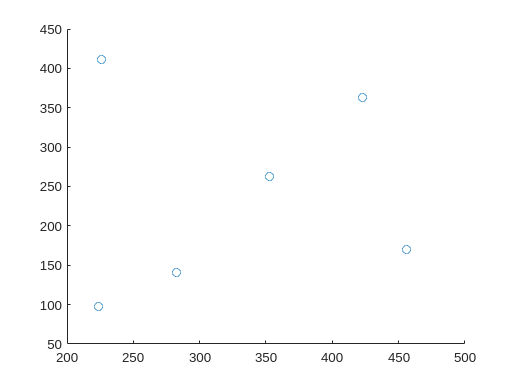


scatter(x,y )

**Step 6.**

By using the 3D points created in Step 3 and their projection obtained

in Step 5, estimate the 3x4 camera projection matrix P by using the

method of Hall.

Q = []


Q =

     []



B = []


B =

     []



for i = 1:point_num
    p2d = points_2d_array(:,i);
    p3d = points_3d_array(:,i);

    Q1 = [p3d(1), p3d(2), p3d(3), 1, 0, 0, 0, 0, -p2d(1)*p3d(1), -p2d(1)*p3d(2), -p2d(1)*p3d(3)];
    Q2 = [0, 0, 0, 0, p3d(1), p3d(2), p3d(3), 1, -p2d(2)*p3d(1), -p2d(2)*p3d(2), - p2d(2)*p3d(3)];

    B1 = [p2d(1)];
    B2 = [p2d(2)];

    Q(2*i-1,:) = Q1;
    Q(2*i,:)   = Q2;
    B(2*i-1,:) = B1;
    B(2*i,:)   = B2;

end
A = inv(Q.'*Q)*Q.'*B

A =    -0.3324
    0.0624
   -0.2662
  363.5215
   -0.1207
    0.4903
    0.1028
  298.6679
    0.0001
    0.0004


P_cal = [A(1), A(2), A(3), A(4);
         A(5), A(6), A(7), A(8);
         A(9), A(10),A(11), 1]

P_cal =    -0.3324    0.0624   -0.2662  363.5215
   -0.1207    0.4903    0.1028  298.6679
    0.0001    0.0004   -0.0005    1.0000


**Step 7.**

Compare the matrix obtained in Step 6 to the one defined in step 2.

Extract the intrinsic parameter matrix K, and the camera rotation matrix

 from the camera projection matrix P (see appendix)

[K_cal,Rcw_cal] = get_intrinsics_from_proj_matrix(P_cal)

K_cal =   557.0943    0.0000  326.3819
         0  712.9824  298.6679
         0         0    1.0000


Rcw_cal =    -0.9511   -0.1816   -0.2500
   -0.2939    0.7817    0.5501
    0.0955    0.5967   -0.7968


K

K =   557.0943         0  326.3819
         0  712.9824  298.6679
         0         0    1.0000


Rcw

Rcw =    -0.9511   -0.1816   -0.2500
   -0.2939    0.7817    0.5501
    0.0955    0.5967   -0.7968


**Step 8.**

Add Gaussian noise to all the 2D points producing discrepancies

between the range [-1,+1] pixels for the 95% of points. You can use the

function normrnd.

% Points in 2D 
points_2d_array_noised = []


points_2d_array_noised =

     []



for i = 1:point_num
    points_2d_array_noised(:,i) =  P*points_3d_array(:,i); 
    points_2d_array_noised(:,i) = points_2d_array_noised(:,i)/points_2d_array_noised(3,i) ; % noramilize

end
% Add noise
noise = randn(size(points_2d_array_noised)); % Generates a random value from a normal distribution with mean 0 and std dev 1
noise = max(min(noise, 1), -1); % Clip values to be between -1 and 1
noise(3,:) = 0

noise =     1.0000    0.6733   -1.0000   -0.0034    0.4704   -0.2134
    0.1076   -0.3959    0.2735   -0.8872    0.0463   -0.4781
         0         0         0         0         0         0


points_2d_array_noised = points_2d_array_noised + noise

points_2d_array_noised =   226.9832  423.2029  281.4109  455.6408  224.2502  352.4141
  411.8488  363.2156  141.2432  169.5202   97.5531  262.2766
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



% Calculate matrix P
Q_n = []


Q_n =

     []



B_n = []


B_n =

     []



for i = 1:point_num
    p2d = points_2d_array_noised(:,i);
    p3d = points_3d_array(:,i);

    Q1 = [p3d(1), p3d(2), p3d(3), 1, 0, 0, 0, 0, -p2d(1)*p3d(1), -p2d(1)*p3d(2), -p2d(1)*p3d(3)];
    Q2 = [0, 0, 0, 0, p3d(1), p3d(2), p3d(3), 1, -p2d(2)*p3d(1), -p2d(2)*p3d(2), - p2d(2)*p3d(3)];

    B1 = [p2d(1)];
    B2 = [p2d(2)];

    Q_n(2*i-1,:) = Q1;
    Q_n(2*i,:)   = Q2;
    B_n(2*i-1,:) = B1;
    B_n(2*i,:)   = B2;

end
A_n = inv(Q_n.'*Q_n)*Q_n.'*B_n

A_n =    -0.3221
    0.0689
   -0.2735
  363.9217
   -0.1128
    0.4960
    0.0983
  298.3089
    0.0001
    0.0004


P_n_cal = [A_n(1), A_n(2), A_n(3), A_n(4);
         A_n(5), A_n(6), A_n(7), A_n(8);
         A_n(9), A_n(10),A_n(11), 1]

P_n_cal =    -0.3221    0.0689   -0.2735  363.9217
   -0.1128    0.4960    0.0983  298.3089
    0.0001    0.0004   -0.0006    1.0000



% Extract K matrix and Rotational matrix
[K_n_cal,Rcw_n_cal] = get_intrinsics_from_proj_matrix(P_n_cal)

K_n_cal =   528.6550    7.3251  296.7433
         0  678.7546  278.2241
         0         0    1.0000


Rcw_n_cal =    -0.9430   -0.1563   -0.2938
   -0.2969    0.7937    0.5309
    0.1502    0.5878   -0.7949


K

K =   557.0943         0  326.3819
         0  712.9824  298.6679
         0         0    1.0000


K_n_cal

K_n_cal =   528.6550    7.3251  296.7433
         0  678.7546  278.2241
         0         0    1.0000


Rcw

Rcw =    -0.9511   -0.1816   -0.2500
   -0.2939    0.7817    0.5501
    0.0955    0.5967   -0.7968


Rcw_n_cal

Rcw_n_cal =    -0.9430   -0.1563   -0.2938
   -0.2969    0.7937    0.5309
    0.1502    0.5878   -0.7949


**Step 9.**

Now compute the 2D points with the projection matrix and compare

them to those obtained in step 4. For this comparison compute the

average projection error.

% Project 3d to 2d points sing calibrated P matrix
points_2d_noise_pojected = []


points_2d_noise_pojected =

     []



for i = 1:point_num
    points_2d_noise_pojected(:,i) =  P_n_cal*points_3d_array(:,i); 
    points_2d_noise_pojected(:,i) = points_2d_noise_pojected(:,i)/points_2d_noise_pojected(3,i) ; % noramilize
end
points_2d_noise_pojected

points_2d_noise_pojected =   226.7934  423.0853  281.7087  455.4214  223.8044  353.0986
  411.6196  363.3845  141.1282  169.3533   97.8094  262.3600
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


x_n = points_2d_noise_pojected(1,:)

x_n =   226.7934  423.0853  281.7087  455.4214  223.8044  353.0986


y_n = points_2d_noise_pojected(2,:)

y_n =   411.6196  363.3845  141.1282  169.3533   97.8094  262.3600


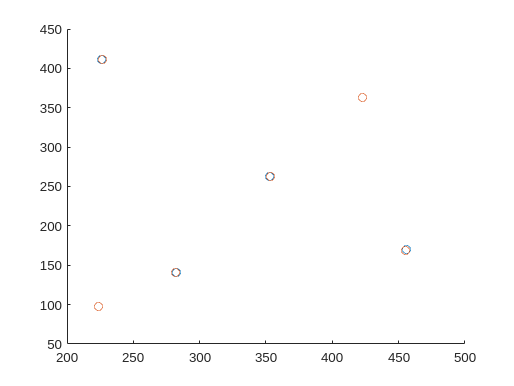


scatter(x,y )
hold on
scatter(x_n,y_n )
hold off

% Compute average projection error
diff = points_2d_noise_pojected - points_2d_array;
ecu_dis = [];
for i=1:point_num
    ecu_dis(end+1) = sqrt(diff(1,i)^2+ diff(2,i)^2 )  ;
end
avg_err_6 = mean(ecu_dis)

avg_err_6 = 0.6892

**Step 10.**

Increase the number of 3D points up to 10 points and then up to 50

points and repeat step 8 and 9.

Confirm that the higher the number of points used, the more accurate

is the obtained projection matrix.

Plot a graph of the average projection error as a function of the number

of points


% 10 points
p_3d_10 = random_3d_points(10,-480,480);
p_2d_10 = points_2d_from_3d(p_3d_10,P);

norm_matrix = 1.0e-03 *

    0.7531    0.7024    0.6514    0.5438    0.5596    0.8496    0.6771    0.5724    0.8246    0.6830
    0.7531    0.7024    0.6514    0.5438    0.5596    0.8496    0.6771    0.5724    0.8246    0.6830
    0.7531    0.7024    0.6514    0.5438    0.5596    0.8496    0.6771    0.5724    0.8246    0.6830


points_2d_array =   394.9304  415.2680  552.7296  222.3365  479.8959  263.9239  346.1726  291.3650  381.9309  537.0683
  596.9906  412.4623  269.0563  360.7982  324.6856   54.9958  186.9718  134.9869  173.9751  300.3864
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


p_2d_10_noised = add_noise_2d(p_2d_10);

num_points = 10

noise =     0.0821   -0.1349   -0.0570   -0.5244   -0.1753    0.0678   -0.0750    0.4274    0.2822    0.0147
    0.1720    0.3053   -0.5100    0.1502   -0.1896   -0.2119   -0.0958   -0.1031    0.0345   -0.2868
         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised =   395.0125  415.1331  552.6726  221.8121  479.7206  263.9916  346.0977  291.7924  382.2132  537.0830
  597.1626  412.7676  268.5463  360.9484  324.4960   54.7839  186.8761  134.8838  174.0096  300.0996
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


P_10 = calibrate_P(p_2d_10_noised,p_3d_10);
p_2d_10_pro =  points_2d_from_3d(p_3d_10, P_10);

norm_matrix =     1.1300    1.0533    0.9753    0.8164    0.8381    1.2764    1.0158    0.8588    1.2374    1.0228
    1.1300    1.0533    0.9753    0.8164    0.8381    1.2764    1.0158    0.8588    1.2374    1.0228
    1.1300    1.0533    0.9753    0.8164    0.8381    1.2764    1.0158    0.8588    1.2374    1.0228


points_2d_array =   394.7238  415.2467  552.6672  221.9606  479.8083  264.0709  346.3257  291.4476  382.2301  537.0501
  597.3120  412.4633  268.7636  361.0136  324.3708   54.7838  186.9185  134.8758  173.9558  300.1144
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = avg_project_error(p_2d_10_pro,p_2d_10 )

avg_err_10 = 0.2593


% 10 points
p_3d_50 = random_3d_points(50,-480,480);
p_2d_50 = points_2d_from_3d(p_3d_50,P);

norm_matrix =     0.0006    0.0009    0.0007    0.0006    0.0005    0.0007    0.0007    0.0006    0.0007    0.0009    0.0007    0.0008    0.0007    0.0010    0.0006    0.0006    0.0008    0.0008    0.0005    0.0006    0.0009    0.0006    0.0006    0.0012    0.0006    0.0007    0.0008    0.0007    0.0009    0.0009    0.0010    0.0005    0.0006    0.0006    0.0007    0.0006    0.0008    0.0007    0.0009    0.0005    0.0006    0.0007    0.0008    0.0006    0.0007    0.0008    0.0007    0.0008    0.0007    0.0008
    0.0006    0.0009    0.0007    0.0006    0.0005    0.0007    0.0007    0.0006    0.0007    0.0009    0.0007    0.0008    0.0007    0.0010    0.0006    0.0006    0.0008    0.0008    0.0005    0.0006    0.0009    0.0006    0.0006    0.0012    0.0006    0.0007    0.0008    0.0007    0.0009    0.0009    0.0010    0.0005    0.0006    0.0006    0.0007    0.0006    0.0008    0.0007    0.0009    0.0005    0.0006    0.0007    0.0008    0.0006    0.0007    0.0008    0.0007    0.0008    0

points_2d_array =   364.2313  229.4058  335.1799  227.1822  411.0260  317.1889  295.1828  331.3053  333.9729  531.5469  392.8733  180.0223  470.6546  325.4658  287.9043  405.5441  568.5362  198.4060  271.7755  370.6982  503.7788  269.8466  451.6371  526.0573  347.9549  485.5208  554.8959  396.9414  632.6845  510.1462  234.5447  402.2152  464.2683  308.9668  410.7148  352.3960  299.1390  245.8242  439.9031  455.1253  511.0950  440.4696  442.0280  308.2312  215.2355  363.4677  222.3029  411.5335  162.3376  424.5468
  399.5972  162.2213  108.0240  338.1301  361.7992  589.7151  455.0429  353.5785  455.0765  217.6931  260.0208  260.5084  545.2162  162.7321  158.3020  342.4420  115.6730  425.1792  187.1163  241.0152  512.8306  204.2398  205.0172  319.9446  265.6087  300.2716  252.1638  169.2175  159.2135  194.7948   82.1075  282.9482  168.1086  110.6806  557.0328  128.0808  215.6133  560.6970  476.8585  301.6124  297.9400  533.1555  311.9554  228.5317  152.4121  255.6940  526.0419  373.3408 

p_2d_50_noised = add_noise_2d(p_2d_50);

num_points = 50

noise =     0.3997   -0.0573   -0.1209   -0.1791   -0.1714    0.1468    0.2210    0.2238    0.4318   -0.1960   -0.2260   -0.0859   -0.3402    0.1474    0.5003   -0.2604   -0.1631   -0.0508   -0.2815    0.2653   -0.2805   -0.1516   -0.2183   -0.1994   -0.4794   -0.0718    0.1275   -0.3531    0.3195    0.0260    0.0356   -0.0421    0.3881   -0.2280    0.2760    0.6441    0.0782   -0.1508   -0.3049    0.2931   -0.2692   -0.1215   -0.4192    0.2480    0.2445   -0.1034   -0.2914    0.1386   -0.1458    0.2033
    0.1062   -0.1912   -0.0366   -0.1053    0.3007   -0.1294   -0.3179    0.3123    0.1288    0.2156    0.3711   -0.1991   -0.1318    0.0758   -0.1145   -0.0164   -0.0674    0.4799   -0.3157   -0.1710   -0.0079   -0.4121    0.1140   -0.2998    0.1072    0.2202    0.3151    0.0862    0.0474    0.4617   -0.3179    0.4202    0.3767   -0.1328   -0.2871   -0.0170    0.0735   -0.0412   -0.2714    0.0969    0.5104   -0.4039   -0.1457   -0.3335   -0.2787   -0.2239   -0.5071    0.1221    0.0393 

points_2d_array_noised =   364.6310  229.3485  335.0590  227.0031  410.8546  317.3357  295.4039  331.5291  334.4047  531.3509  392.6472  179.9364  470.3144  325.6132  288.4046  405.2837  568.3731  198.3553  271.4941  370.9636  503.4983  269.6949  451.4189  525.8579  347.4755  485.4490  555.0234  396.5883  633.0041  510.1722  234.5803  402.1730  464.6564  308.7387  410.9908  353.0401  299.2172  245.6735  439.5982  455.4184  510.8259  440.3481  441.6088  308.4792  215.4800  363.3643  222.0115  411.6721  162.1919  424.7501
  399.7034  162.0301  107.9874  338.0247  362.0998  589.5858  454.7250  353.8908  455.2053  217.9087  260.3919  260.3093  545.0844  162.8079  158.1875  342.4256  115.6056  425.6590  186.8006  240.8442  512.8228  203.8277  205.1312  319.6448  265.7159  300.4918  252.4789  169.3036  159.2609  195.2565   81.7896  283.3684  168.4853  110.5478  556.7456  128.0638  215.6868  560.6558  476.5870  301.7093  298.4504  532.7516  311.8097  228.1982  152.1333  255.4701  525.5348  37

P_50 = calibrate_P(p_2d_50_noised,p_3d_50);
p_2d_50_pro =  points_2d_from_3d(p_3d_50, P_50);

norm_matrix =     0.9536    1.3188    1.0155    0.8923    0.7822    1.0231    1.0266    0.9196    1.0362    1.3947    1.0931    1.1780    0.9954    1.4709    0.9393    0.9217    1.1657    1.1897    0.7676    0.9328    1.2873    0.8622    0.8740    1.7389    0.8273    0.9898    1.2589    0.9878    1.2986    1.3156    1.4686    0.7801    0.9505    0.8383    1.0608    0.8355    1.1492    1.0347    1.4068    0.7594    0.8315    1.0836    1.1271    0.9361    0.9901    1.1669    1.0933    1.1986    1.0983    1.1345
    0.9536    1.3188    1.0155    0.8923    0.7822    1.0231    1.0266    0.9196    1.0362    1.3947    1.0931    1.1780    0.9954    1.4709    0.9393    0.9217    1.1657    1.1897    0.7676    0.9328    1.2873    0.8622    0.8740    1.7389    0.8273    0.9898    1.2589    0.9878    1.2986    1.3156    1.4686    0.7801    0.9505    0.8383    1.0608    0.8355    1.1492    1.0347    1.4068    0.7594    0.8315    1.0836    1.1271    0.9361    0.9901    1.1669    1.0933    1.1986    1

points_2d_array =   364.2275  229.4366  335.2566  227.1013  411.0007  317.1746  295.1910  331.3086  333.9779  531.5210  392.9354  179.9553  470.4663  325.6170  287.9029  405.5449  568.5746  198.4188  271.7051  370.7449  503.5485  269.7996  451.6968  525.9318  347.9675  485.4940  554.8037  397.0309  632.5385  510.1753  234.6180  402.2292  464.3525  308.9739  410.6207  352.4513  299.1973  245.8336  439.8353  455.1146  511.0440  440.3455  442.0399  308.2455  215.1307  363.5450  222.3205  411.5442  162.3003  424.5799
  399.6613  161.9464  107.8628  338.1223  361.9672  589.5244  455.0169  353.6453  455.0560  217.8735  260.0840  260.3118  545.0903  162.5945  158.1495  342.5640  115.9355  425.0634  187.0065  241.0766  512.6139  204.1418  205.1702  319.9352  265.6829  300.4543  252.3799  169.2460  159.5768  194.9639   81.7055  283.1015  168.2441  110.4822  556.8553  127.9921  215.5243  560.5632  476.6540  301.8279  298.1900  533.0082  312.0555  228.5036  152.1274  255.7065  525.9165  373.3572 

avg_err_50 = avg_project_error(p_2d_50_pro,p_2d_50 )

avg_err_50 = 0.1584


% Plot Graph
point_nums = [6,10,50]

point_nums =      6    10    50


err = [avg_err_6,avg_err_10,avg_err_50]

err =     0.6892    0.2593    0.1584


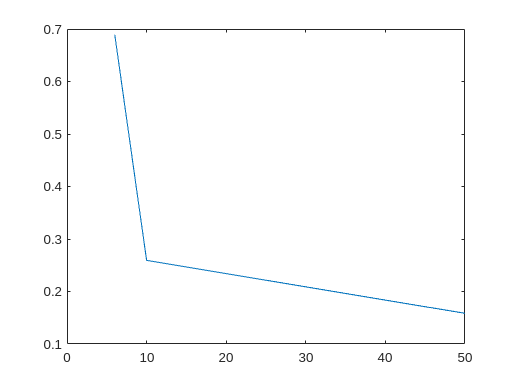

plot(point_nums,err)

Plot everything

err = []


err =

     []



points_num = []


points_num =

     []



for i=6:100
    p_3d_10 = random_3d_points(i,-480,480);
    p_2d_10 = points_2d_from_3d(p_3d_10,P);
    p_2d_10_noised = add_noise_2d(p_2d_10);
    P_10 = calibrate_P(p_2d_10_noised,p_3d_10);
    p_2d_10_pro =  points_2d_from_3d(p_3d_10, P_10);
    avg_err_10 = avg_project_error(p_2d_10_pro,p_2d_10 )
    err(end+1) = avg_err_10
    points_num(end+1) = i
end

norm_matrix = 1.0e-03 *

    0.4982    0.6554    0.5922    0.6877    0.7490    0.6397
    0.4982    0.6554    0.5922    0.6877    0.7490    0.6397
    0.4982    0.6554    0.5922    0.6877    0.7490    0.6397


points_2d_array =   334.8075  245.7841  346.5630  276.8715  324.3826  308.3482
  239.0305  219.9714  469.5444  378.1461  162.2520  417.0407
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 6

noise =     0.6118   -0.2276   -0.1534    0.2297    0.0665   -0.0131
   -0.0217    0.2234   -0.1143   -0.3477   -0.0973   -0.1304
         0         0         0         0         0         0


points_2d_array_noised =   335.4192  245.5565  346.4096  277.1012  324.4491  308.3351
  239.0088  220.1948  469.4301  377.7984  162.1548  416.9103
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix =     0.7754    1.0086    0.9033    1.0453    1.1156    0.9748
    0.7754    1.0086    0.9033    1.0453    1.1156    0.9748
    0.7754    1.0086    0.9033    1.0453    1.1156    0.9748


points_2d_array =   335.4192  245.5563  346.4076  277.0982  324.4492  308.3403
  239.0087  220.1952  469.4305  377.7979  162.1548  416.9100
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.2981

err = 0.2981

points_num = 6

norm_matrix = 1.0e-03 *

    0.6177    0.6991    0.5653    0.7144    0.5359    0.5086    0.5018
    0.6177    0.6991    0.5653    0.7144    0.5359    0.5086    0.5018
    0.6177    0.6991    0.5653    0.7144    0.5359    0.5086    0.5018


points_2d_array =   322.0353  356.0524  488.5766  184.2338  252.3521  445.4276  324.7146
  465.7213  581.9105  435.7530  333.7070  158.0957  306.1352  322.8102
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 7

noise = 3×7
    0.1785    0.5261    0.1674   -0.1861   -0.4582   -0.1760   -0.1405
    0.1411    0.1764   -0.0897    0.0317    0.0731    0.4647   -0.1859
         0         0         0         0         0         0         0


points_2d_array_noised = 3×7
  322.2138  356.5785  488.7440  184.0477  251.8938  445.2516  324.5741
  465.8623  582.0869  435.6633  333.7387  158.1688  306.5999  322.6243
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×7
    0.9344    1.0560    0.8502    1.0788    0.8088    0.7654    0.7596
    0.9344    1.0560    0.8502    1.0788    0.8088    0.7654    0.7596
    0.9344    1.0560    0.8502    1.0788    0.8088    0.7654    0.7596


points_2d_array = 3×7
  322.2205  356.6631  488.6435  184.0013  251.9037  445.3288  324.5445
  465.8797  582.0678  435.7270  333.7070  158.2080  306.5352  322.6167
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.3301

err = 1×2
    0.2981    0.3301


points_num = 1×2
     6     7


norm_matrix = 3×8
1.0e-03 *

    0.7413    0.6338    0.6126    0.7810    0.7280    0.7067    0.4963    0.5941
    0.7413    0.6338    0.6126    0.7810    0.7280    0.7067    0.4963    0.5941
    0.7413    0.6338    0.6126    0.7810    0.7280    0.7067    0.4963    0.5941


points_2d_array = 3×8
  406.9709  311.5251  365.9823  444.1478  271.8393  569.2920  322.2068  259.2236
  181.9395   18.1488  163.9905  633.4525  287.9453  187.5155  239.2597  375.9287
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 8

noise = 3×8
    0.0297    0.0659   -0.1167    0.3555   -0.3227   -0.0087    0.1464    0.1558
    0.6849   -0.6932    0.0801   -0.2075    0.2687   -0.0252    0.0838    0.0746
         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×8
  407.0007  311.5911  365.8657  444.5033  271.5166  569.2833  322.3532  259.3794
  182.6244   17.4557  164.0705  633.2450  288.2140  187.4902  239.3435  376.0033
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×8
    1.1138    0.9531    0.9193    1.1690    1.0943    1.0593    0.7432    0.8905
    1.1138    0.9531    0.9193    1.1690    1.0943    1.0593    0.7432    0.8905
    1.1138    0.9531    0.9193    1.1690    1.0943    1.0593    0.7432    0.8905


points_2d_array = 3×8
  407.0983  311.3142  366.0230  444.3066  271.6909  569.3185  322.3484  259.3918
  182.0917   17.6036  164.0484  633.2491  288.3805  187.7251  239.2612  376.0749
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.2684

err = 1×3
    0.2981    0.3301    0.2684


points_num = 1×3
     6     7     8


norm_matrix = 3×9
1.0e-03 *

    0.5241    0.5906    0.6155    0.6343    0.5928    0.6367    0.7576    0.5393    0.6790
    0.5241    0.5906    0.6155    0.6343    0.5928    0.6367    0.7576    0.5393    0.6790
    0.5241    0.5906    0.6155    0.6343    0.5928    0.6367    0.7576    0.5393    0.6790


points_2d_array = 3×9
  292.2327  333.7151  172.7471  298.2003  421.8535  299.5101  260.6420  227.6054  366.7594
  346.0847  413.7956  379.5269  520.6610  139.0502   39.0307  234.4062  279.8481  247.5748
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 9

noise = 3×9
    0.2305   -0.0935    0.0290   -0.0637    0.2191   -0.3444    0.0144   -0.0540    0.1463
    0.0511   -0.0357    0.2032    0.6901   -0.0934   -0.7137   -0.6670   -0.1328   -0.0498
         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×9
  292.4633  333.6216  172.7761  298.1365  422.0726  299.1657  260.6564  227.5515  366.9057
  346.1358  413.7599  379.7302  521.3511  138.9568   38.3170  233.7392  279.7153  247.5250
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×9
    0.7836    0.8844    0.9223    0.9508    0.8876    0.9544    1.1390    0.8067    1.0188
    0.7836    0.8844    0.9223    0.9508    0.8876    0.9544    1.1390    0.8067    1.0188
    0.7836    0.8844    0.9223    0.9508    0.8876    0.9544    1.1390    0.8067    1.0188


points_2d_array = 3×9
  292.2852  333.7945  172.6203  298.2860  421.8895  299.4368  260.4379  227.6619  366.9267
  346.1049  414.0012  379.5900  521.2224  138.8957   38.2992  233.9318  279.7928  247.3990
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.3020

err = 1×4
    0.2981    0.3301    0.2684    0.3020


points_num = 1×4
     6     7     8     9


norm_matrix = 3×10
1.0e-03 *

    0.7201    0.8954    0.5814    0.5578    0.4925    0.8419    0.5984    0.6649    0.6748    0.5705
    0.7201    0.8954    0.5814    0.5578    0.4925    0.8419    0.5984    0.6649    0.6748    0.5705
    0.7201    0.8954    0.5814    0.5578    0.4925    0.8419    0.5984    0.6649    0.6748    0.5705


points_2d_array = 3×10
  512.7049  246.0617  285.3477  276.9263  305.3537  345.0176  506.6340  234.8668  524.4572  215.9965
  230.0769  245.7720  183.8741  186.8878  240.8996  119.9806  216.1853  141.3326  392.4622  390.7604
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 10

noise = 3×10
    0.1194   -0.2838    0.4492   -0.1147   -0.1833    0.2245   -0.0178   -0.1538    0.0211   -0.0123
    0.3962   -0.0274   -0.0118    0.1239    0.2177   -0.0060   -0.0232    0.3676    0.0542   -0.1182
         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×10
  512.8243  245.7778  285.7969  276.8117  305.1704  345.2421  506.6162  234.7130  524.4783  215.9842
  230.4731  245.7447  183.8623  187.0117  241.1173  119.9746  216.1621  141.7002  392.5164  390.6422
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×10
    1.0807    1.3454    0.8716    0.8361    0.7378    1.2647    0.8972    0.9974    1.0124    0.8550
    1.0807    1.3454    0.8716    0.8361    0.7378    1.2647    0.8972    0.9974    1.0124    0.8550
    1.0807    1.3454    0.8716    0.8361    0.7378    1.2647    0.8972    0.9974    1.0124    0.8550


points_2d_array = 3×10
  512.8867  245.9249  285.3531  276.9360  305.3166  345.1455  506.6228  234.8680  524.4447  215.9347
  230.2077  245.8984  184.0495  187.0685  241.0076  119.9871  216.3328  141.4920  392.5237  390.6412
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1513

err = 1×5
    0.2981    0.3301    0.2684    0.3020    0.1513


points_num = 1×5
     6     7     8     9    10


norm_matrix = 3×11
1.0e-03 *

    0.7716    0.6437    0.4945    0.7546    0.6066    0.7135    0.9208    0.8538    0.8996    0.7333    0.7003
    0.7716    0.6437    0.4945    0.7546    0.6066    0.7135    0.9208    0.8538    0.8996    0.7333    0.7003
    0.7716    0.6437    0.4945    0.7546    0.6066    0.7135    0.9208    0.8538    0.8996    0.7333    0.7003


points_2d_array = 3×11
  380.3991  436.3232  415.2376  415.9051  206.1514  269.7247  506.8928  589.0054  306.3642  371.1161  422.3803
  551.5772  249.6920  322.9136   82.4283  274.6353  212.5704  396.7136  283.3041  289.9343  161.5880  473.9871
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 11

noise = 3×11
    0.0429   -0.0722   -0.4090    0.2804   -0.0380    0.0628   -0.0126   -0.0647    0.2024    0.2846   -0.1924
    0.4761    0.1174    0.1277    0.1222    0.0335   -0.2157    0.4428    0.0327   -0.0513   -0.2687   -0.0888
         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×11
  380.4420  436.2510  414.8286  416.1855  206.1134  269.7875  506.8802  588.9406  306.5667  371.4007  422.1879
  552.0533  249.8095  323.0413   82.5505  274.6688  212.3547  397.1564  283.3368  289.8830  161.3193  473.8982
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×11
    1.1589    0.9642    0.7393    1.1324    0.9113    1.0725    1.3832    1.2797    1.3551    1.1008    1.0500
    1.1589    0.9642    0.7393    1.1324    0.9113    1.0725    1.3832    1.2797    1.3551    1.1008    1.0500
    1.1589    0.9642    0.7393    1.1324    0.9113    1.0725    1.3832    1.2797    1.3551    1.1008    1.0500


points_2d_array = 3×11
  380.3311  436.2011  414.8560  416.2052  206.1199  269.8305  507.1550  588.8177  306.5060  371.3620  422.2123
  552.0004  249.8653  322.9863   82.3765  274.6248  212.4027  396.9323  283.4243  289.8807  161.5152  474.0418
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.2467

err = 1×6
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467


points_num = 1×6
     6     7     8     9    10    11


norm_matrix = 3×12
    0.0007    0.0005    0.0007    0.0011    0.0007    0.0009    0.0006    0.0006    0.0005    0.0008    0.0007    0.0005
    0.0007    0.0005    0.0007    0.0011    0.0007    0.0009    0.0006    0.0006    0.0005    0.0008    0.0007    0.0005
    0.0007    0.0005    0.0007    0.0011    0.0007    0.0009    0.0006    0.0006    0.0005    0.0008    0.0007    0.0005


points_2d_array = 3×12
  278.4247  229.3284  470.3571  380.9660  263.6745  612.0772  459.9242  496.6902  288.9142  390.9713  384.2941  461.2437
  482.2045  246.5307  475.9123  296.1864  238.0282  277.8780  417.8476  308.7079  305.8713  338.8216  232.4678  388.0640
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 12

noise = 3×12
   -0.1594   -0.0707   -0.2752    0.2730   -0.2790   -0.0076    0.2201   -0.2766   -0.2210   -0.2112    0.1256   -0.3986
    0.1052   -0.3391   -0.1945   -0.0069   -0.0483   -0.0462   -0.0262   -0.3010   -0.3871   -0.0870   -0.2227   -0.3150
         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×12
  278.2653  229.2577  470.0819  381.2390  263.3955  612.0696  460.1443  496.4137  288.6932  390.7601  384.4197  460.8451
  482.3097  246.1916  475.7177  296.1796  237.9799  277.8317  417.8214  308.4069  305.4843  338.7345  232.2452  387.7490
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×12
    1.0522    0.8246    1.0159    1.5971    1.0126    1.3609    0.9463    0.8873    0.7767    1.2095    1.1163    0.8145
    1.0522    0.8246    1.0159    1.5971    1.0126    1.3609    0.9463    0.8873    0.7767    1.2095    1.1163    0.8145
    1.0522    0.8246    1.0159    1.5971    1.0126    1.3609    0.9463    0.8873    0.7767    1.2095    1.1163    0.8145


points_2d_array = 3×12
  278.2386  229.1719  470.2405  381.1576  263.5710  612.1079  459.7544  496.4273  288.7242  390.9654  384.2481  460.9783
  482.2918  246.2264  475.8232  296.2825  237.7972  277.8242  417.6487  308.4269  305.5570  338.7596  232.2866  387.7499
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.2415

err = 1×7
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415


points_num = 1×7
     6     7     8     9    10    11    12


norm_matrix = 3×13
    0.0006    0.0009    0.0005    0.0008    0.0006    0.0007    0.0007    0.0009    0.0008    0.0010    0.0006    0.0007    0.0008
    0.0006    0.0009    0.0005    0.0008    0.0006    0.0007    0.0007    0.0009    0.0008    0.0010    0.0006    0.0007    0.0008
    0.0006    0.0009    0.0005    0.0008    0.0006    0.0007    0.0007    0.0009    0.0008    0.0010    0.0006    0.0007    0.0008


points_2d_array = 3×13
  296.0007  308.7496  304.9531  457.6657  389.4543  352.8536  367.0972  162.4717  359.0064  258.3338  330.1331  218.3524  288.5863
  173.8537  185.7874  312.7157  106.8878  306.8694  209.2211  611.0855  292.7779  304.7914  113.0416  110.1307  514.2138   90.9265
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 13

noise = 3×13
    0.1963   -0.1614    0.2933   -0.1660   -0.0561   -0.0876   -0.3724    0.0264    0.0011   -0.3245   -0.4316    0.2148    0.3538
    0.1939    0.1159   -0.0050   -0.7925    0.0171    0.3440    0.1061   -0.0498   -0.2452   -0.0624    0.0608   -0.2024    0.1285
         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×13
  296.1970  308.5882  305.2465  457.4997  389.3981  352.7661  366.7248  162.4981  359.0075  258.0093  329.7016  218.5672  288.9402
  174.0476  185.9033  312.7107  106.0953  306.8865  209.5651  611.1915  292.7281  304.5462  112.9792  110.1915  514.0114   91.0550
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×13
    0.8603    1.3960    0.8112    1.2247    0.9389    1.0125    1.0871    1.3800    1.2682    1.5067    0.8557    1.1172    1.1507
    0.8603    1.3960    0.8112    1.2247    0.9389    1.0125    1.0871    1.3800    1.2682    1.5067    0.8557    1.1172    1.1507
    0.8603    1.3960    0.8112    1.2247    0.9389    1.0125    1.0871    1.3800    1.2682    1.5067    0.8557    1.1172    1.1507


points_2d_array = 3×13
  296.1089  308.5294  305.0508  457.5768  389.3085  352.7413  366.9122  162.7251  358.7969  258.1218  330.1368  218.6015  288.5467
  174.0641  185.6708  312.7449  106.3068  306.8447  209.2086  611.1826  292.9190  304.7794  112.9067  110.3018  514.0042   90.9867
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.2281

err = 1×8
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281


points_num = 1×8
     6     7     8     9    10    11    12    13


norm_matrix = 3×14
1.0e-03 *

    0.6721    0.5876    0.4737    0.6792    0.6594    0.7895    0.5081    0.9532    0.6062    0.6240    0.6245    0.8212    0.6865    0.5678
    0.6721    0.5876    0.4737    0.6792    0.6594    0.7895    0.5081    0.9532    0.6062    0.6240    0.6245    0.8212    0.6865    0.5678
    0.6721    0.5876    0.4737    0.6792    0.6594    0.7895    0.5081    0.9532    0.6062    0.6240    0.6245    0.8212    0.6865    0.5678


points_2d_array = 3×14
  423.6140  522.9596  265.8552  384.9289  385.9178  203.0666  252.6780  499.3664  468.1863  446.5444  467.9950  552.5550  469.6780  256.7843
  383.4051  270.4997  313.1539  310.7025  229.1546   29.4655  259.8093  269.1707  217.8576  432.1452  239.0759  163.1403  196.4510  153.1191
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 14

noise = 3×14
    0.1494   -0.6454   -0.1983   -0.3284    0.5865    0.4449    0.2967    0.0425   -0.0730   -0.0852   -0.0081    0.1384   -0.1936    0.4525
   -0.4284    0.2389   -0.2953    0.2492   -0.1745   -0.4081   -0.2094   -0.2714    0.0052   -0.1823   -0.0062    0.1764   -0.0160   -0.2072
         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×14
  423.7634  522.3142  265.6570  384.6005  386.5043  203.5115  252.9747  499.4089  468.1133  446.4592  467.9869  552.6934  469.4844  257.2369
  382.9768  270.7386  312.8586  310.9517  228.9801   29.0574  259.6000  268.8993  217.8629  431.9629  239.0697  163.3168  196.4350  152.9119
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×14
    1.0081    0.8788    0.7104    1.0187    0.9882    1.1852    0.7620    1.4302    0.9071    0.9358    0.9348    1.2289    1.0276    0.8511
    1.0081    0.8788    0.7104    1.0187    0.9882    1.1852    0.7620    1.4302    0.9071    0.9358    0.9348    1.2289    1.0276    0.8511
    1.0081    0.8788    0.7104    1.0187    0.9882    1.1852    0.7620    1.4302    0.9071    0.9358    0.9348    1.2289    1.0276    0.8511


points_2d_array = 3×14
  423.5381  522.5315  265.8597  384.9965  386.0954  203.6299  252.8021  499.6573  468.0816  446.3261  467.8986  552.4529  469.6977  257.1763
  383.2262  270.5189  312.9164  310.5059  229.0434   28.9482  259.5705  268.9939  217.9604  431.9508  239.0980  163.3810  196.5486  152.9731
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.2835

err = 1×9
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835


points_num = 1×9
     6     7     8     9    10    11    12    13    14


norm_matrix = 3×15
    0.0005    0.0005    0.0012    0.0006    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0008    0.0006    0.0006    0.0008    0.0006
    0.0005    0.0005    0.0012    0.0006    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0008    0.0006    0.0006    0.0008    0.0006
    0.0005    0.0005    0.0012    0.0006    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0008    0.0006    0.0006    0.0008    0.0006


points_2d_array = 3×15
  267.2777  443.9117  610.3603  299.8383  466.0095  324.8401  385.2318  551.5409  450.0559  509.6090  403.9910  228.0400  277.3733  465.4160  234.5050
  241.6314  346.7020  373.5747  235.7557  486.6353  454.8040  304.8966  350.5025  102.1566  525.3394  326.9875  271.7176  302.7612  471.7670  493.8965
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 15

noise = 3×15
    0.0793   -0.0214    0.3383   -0.2373   -0.3882   -0.1435   -0.0139    0.0399    0.0747   -0.0559   -0.4674   -0.0320    0.0151    0.2769    0.0570
   -0.3924    0.0501   -0.2523    0.0494   -0.0711   -0.4171    0.1979   -0.1839   -0.3591    0.1012   -0.0054    0.1258   -0.2721   -0.0124    0.1830
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×15
  267.3571  443.8903  610.6986  299.6010  465.6212  324.6967  385.2179  551.5808  450.1306  509.5531  403.5236  228.0081  277.3884  465.6930  234.5620
  241.2390  346.7521  373.3224  235.8050  486.5642  454.3869  305.0945  350.3186  101.7975  525.4406  326.9821  271.8434  302.4891  471.7546  494.0795
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×15
    0.7290    0.7774    1.7456    0.8678    0.9923    0.9349    0.8789    1.1470    0.9305    1.1018    1.1259    0.8312    0.8443    1.2453    0.9716
    0.7290    0.7774    1.7456    0.8678    0.9923    0.9349    0.8789    1.1470    0.9305    1.1018    1.1259    0.8312    0.8443    1.2453    0.9716
    0.7290    0.7774    1.7456    0.8678    0.9923    0.9349    0.8789    1.1470    0.9305    1.1018    1.1259    0.8312    0.8443    1.2453    0.9716


points_2d_array = 3×15
  267.2911  443.8496  610.6796  299.7683  465.8911  324.7777  385.1743  551.5387  450.0594  509.4779  403.8847  227.9993  277.3335  465.3072  234.4628
  241.5606  346.6559  373.5452  235.6217  486.5953  454.7453  304.8205  350.4388  101.7753  525.3400  326.8879  271.6232  302.6842  471.8159  493.8288
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1358

err = 1×10
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358


points_num = 1×10
     6     7     8     9    10    11    12    13    14    15


norm_matrix = 3×16
    0.0005    0.0007    0.0007    0.0010    0.0006    0.0008    0.0006    0.0006    0.0008    0.0010    0.0006    0.0007    0.0006    0.0008    0.0005    0.0006
    0.0005    0.0007    0.0007    0.0010    0.0006    0.0008    0.0006    0.0006    0.0008    0.0010    0.0006    0.0007    0.0006    0.0008    0.0005    0.0006
    0.0005    0.0007    0.0007    0.0010    0.0006    0.0008    0.0006    0.0006    0.0008    0.0010    0.0006    0.0007    0.0006    0.0008    0.0005    0.0006


points_2d_array = 3×16
  360.5608  134.2105  280.1188  241.9648  539.7719  403.5371  194.0930  266.1603  442.6909  480.5334  341.4122  334.9310  394.5972  319.2587  230.9322  310.5981
  325.0089  429.4399   38.7412  200.8387  231.5596   91.8110  414.1870  194.4969  402.1383  296.3346  276.2919  612.3550  371.0000  393.0781  243.6401  283.4536
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 16

noise = 3×16
   -0.1015   -0.2642    0.0204    0.4796    0.2157   -0.1572   -0.1056    0.3357    0.2049    0.3687    0.1343   -0.6645    0.2844   -0.3358    0.6750   -0.2165
    0.1781    0.0440    0.3594   -0.4637    0.4181    0.0930   -0.1495   -0.1652   -0.0092    0.1310    0.0499    0.1964   -0.1790   -0.5852    0.3667    0.2735
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×16
  360.4593  133.9463  280.1393  242.4444  539.9876  403.3799  193.9874  266.4960  442.8958  480.9022  341.5465  334.2665  394.8816  318.9229  231.6073  310.3817
  325.1871  429.4839   39.1006  200.3750  231.9777   91.9040  414.0375  194.3317  402.1290  296.4655  276.3418  612.5514  370.8210  392.4929  244.0067  283.7272
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×16
    0.7860    1.1112    1.0625    1.5562    0.9399    1.1291    0.9702    0.8501    1.1525    1.5199    0.9474    1.0714    0.9193    1.2268    0.8160    0.9644
    0.7860    1.1112    1.0625    1.5562    0.9399    1.1291    0.9702    0.8501    1.1525    1.5199    0.9474    1.0714    0.9193    1.2268    0.8160    0.9644
    0.7860    1.1112    1.0625    1.5562    0.9399    1.1291    0.9702    0.8501    1.1525    1.5199    0.9474    1.0714    0.9193    1.2268    0.8160    0.9644


points_2d_array = 3×16
  360.6125  134.0199  280.4959  241.8474  539.9014  403.7520  194.0263  266.4452  442.6843  480.7184  341.4872  334.5849  394.5781  319.1043  231.2160  310.6712
  325.1241  429.2016   39.1033  200.4069  231.7782   91.9688  414.0333  194.7284  402.1901  296.1385  276.3535  612.5830  371.0591  392.9847  243.7805  283.4779
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.2454

err = 1×11
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454


points_num = 1×11
     6     7     8     9    10    11    12    13    14    15    16


norm_matrix = 3×17
    0.0006    0.0008    0.0005    0.0007    0.0005    0.0006    0.0008    0.0009    0.0007    0.0006    0.0009    0.0012    0.0008    0.0006    0.0007    0.0008    0.0005
    0.0006    0.0008    0.0005    0.0007    0.0005    0.0006    0.0008    0.0009    0.0007    0.0006    0.0009    0.0012    0.0008    0.0006    0.0007    0.0008    0.0005
    0.0006    0.0008    0.0005    0.0007    0.0005    0.0006    0.0008    0.0009    0.0007    0.0006    0.0009    0.0012    0.0008    0.0006    0.0007    0.0008    0.0005


points_2d_array = 3×17
  471.0653  324.7495  504.3527  315.5343  399.7185  317.3575  158.6161  555.1524  475.2171  414.6510  392.6936  569.7482  449.4455  387.7521  408.9457  348.7782  271.6561
  158.6619  422.9274  324.5409  511.5949  307.3017  422.8761  381.1740  432.6639  627.5048  172.3607  334.9503  308.5423  582.3304  234.0398  461.8829  459.6045  354.8056
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 17

noise = 3×17
   -0.0863   -0.4678   -0.1204    0.0872   -0.4695    0.4432   -0.5038   -0.1237    0.0614    0.3539   -0.4883   -0.4802    0.1639   -0.1420    0.0592   -0.3839    0.0429
   -0.2054   -0.2194    0.2593    0.2415    0.1451   -0.0351   -0.2531   -0.2763    0.5182   -0.3229   -0.0483   -0.2591    0.2061    0.7388    0.0604    0.4127   -0.2445
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×17
  470.9790  324.2817  504.2324  315.6215  399.2491  317.8007  158.1123  555.0287  475.2785  415.0049  392.2053  569.2680  449.6094  387.6101  409.0049  348.3943  271.6990
  158.4565  422.7080  324.8002  511.8364  307.4468  422.8410  380.9209  432.3877  628.0230  172.0378  334.9020  308.2831  582.5366  234.7785  461.9433  460.0172  354.5612
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×17
    0.8581    1.2584    0.7762    1.0897    0.7808    0.9615    1.1603    1.3210    1.0285    0.9658    1.3301    1.8036    1.1318    0.8640    1.0991    1.1482    0.7669
    0.8581    1.2584    0.7762    1.0897    0.7808    0.9615    1.1603    1.3210    1.0285    0.9658    1.3301    1.8036    1.1318    0.8640    1.0991    1.1482    0.7669
    0.8581    1.2584    0.7762    1.0897    0.7808    0.9615    1.1603    1.3210    1.0285    0.9658    1.3301    1.8036    1.1318    0.8640    1.0991    1.1482    0.7669


points_2d_array = 3×17
  470.9043  324.5232  504.2782  315.4620  399.7108  317.3204  158.2416  555.0183  475.2625  414.4788  392.4367  569.5077  449.4353  387.6671  408.8766  348.6593  271.7102
  158.7106  422.8813  324.7867  511.7424  307.4250  422.9381  380.9450  432.7934  627.8727  172.2363  334.7617  308.1859  582.6412  234.0312  462.0178  459.6786  354.8438
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.2193

err = 1×12
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193


points_num = 1×12
     6     7     8     9    10    11    12    13    14    15    16    17


norm_matrix = 3×18
1.0e-03 *

    0.7629    0.5917    0.6375    0.6805    0.6547    0.7416    0.8858    0.8934    0.8731    0.6384    0.7957    0.5707    0.6080    0.9592    0.5591    0.5294    0.5694    0.6029
    0.7629    0.5917    0.6375    0.6805    0.6547    0.7416    0.8858    0.8934    0.8731    0.6384    0.7957    0.5707    0.6080    0.9592    0.5591    0.5294    0.5694    0.6029
    0.7629    0.5917    0.6375    0.6805    0.6547    0.7416    0.8858    0.8934    0.8731    0.6384    0.7957    0.5707    0.6080    0.9592    0.5591    0.5294    0.5694    0.6029


points_2d_array = 3×18
  321.5558  278.2678  256.9679  479.4845  498.7710  562.5234  284.2871  455.8625  159.7734  369.9021  296.2976  310.5885  340.0132  449.3192  489.0822  323.1598  470.0249  415.9306
  374.2578  435.1513  290.2010  113.9563  426.0201  214.1824  207.9781  399.0861  203.3147  256.9634  172.1043  160.8516  286.3531  321.0550  322.9232  178.7814  402.1749  347.9428
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 18

noise = 3×18
    0.0231    0.0480   -0.1798   -0.6072   -0.0276   -0.4353    0.0155    0.1998   -0.2017   -0.0319    0.2349   -0.3564   -0.4388   -0.1544    0.2978    0.2119    0.1416   -0.0441
   -0.1062    0.0745   -0.3529    0.2361    0.4188   -0.0218   -0.3270    0.1597   -0.3759    0.1278    0.0664    0.2332    0.1513   -0.0292    0.6589    0.4054   -0.2538   -0.0079
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×18
  321.5790  278.3158  256.7882  478.8773  498.7434  562.0881  284.3026  456.0623  159.5717  369.8702  296.5325  310.2321  339.5744  449.1648  489.3800  323.3716  470.1665  415.8865
  374.1515  435.2259  289.8481  114.1924  426.4389  214.1606  207.6512  399.2458  202.9388  257.0912  172.1707  161.0848  286.5044  321.0258  323.5820  179.1868  401.9211  347.9349
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×18
    1.1452    0.8882    0.9561    1.0195    0.9830    1.1121    1.3285    1.3420    1.3092    0.9572    1.1927    0.8548    0.9118    1.4403    0.8387    0.7930    0.8547    0.9046
    1.1452    0.8882    0.9561    1.0195    0.9830    1.1121    1.3285    1.3420    1.3092    0.9572    1.1927    0.8548    0.9118    1.4403    0.8387    0.7930    0.8547    0.9046
    1.1452    0.8882    0.9561    1.0195    0.9830    1.1121    1.3285    1.3420    1.3092    0.9572    1.1927    0.8548    0.9118    1.4403    0.8387    0.7930    0.8547    0.9046


points_2d_array = 3×18
  321.5000  278.2995  256.9426  479.0563  498.9422  562.2471  284.0895  455.9308  159.6589  369.7950  296.1237  310.4977  339.9587  449.2458  489.0427  323.0778  470.1288  415.9286
  374.1495  435.1816  290.1099  114.3707  426.2646  214.3794  207.7292  399.0794  202.9599  257.0217  172.0367  161.1143  286.3835  320.8836  323.1467  179.0608  402.4055  348.0488
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.2203

err = 1×13
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203


points_num = 1×13
     6     7     8     9    10    11    12    13    14    15    16    17    18


norm_matrix = 3×19
    0.0008    0.0007    0.0005    0.0007    0.0005    0.0006    0.0007    0.0006    0.0010    0.0008    0.0007    0.0005    0.0008    0.0005    0.0007    0.0008    0.0005    0.0006    0.0007
    0.0008    0.0007    0.0005    0.0007    0.0005    0.0006    0.0007    0.0006    0.0010    0.0008    0.0007    0.0005    0.0008    0.0005    0.0007    0.0008    0.0005    0.0006    0.0007
    0.0008    0.0007    0.0005    0.0007    0.0005    0.0006    0.0007    0.0006    0.0010    0.0008    0.0007    0.0005    0.0008    0.0005    0.0007    0.0008    0.0005    0.0006    0.0007


points_2d_array = 3×19
  258.1192  416.3627  258.8482  228.1432  282.6474  367.3023  318.9679  328.1937  442.4070  284.1338  333.3845  340.3865  226.8038  496.1113  475.3559  489.8716  315.0163  290.2792  337.5285
   42.4312   77.0834  168.2754  252.4232  182.8239  155.6645  453.4293  233.9873  407.8428  460.8682  127.4985  247.1459  369.5141  312.0661  302.8696  489.8373  296.9126  173.4310  172.3154
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 19

noise = 3×19
    0.0720    0.2327    0.3776   -0.1497   -0.5270    0.0137   -0.1739    0.4201   -0.1797    0.0540    0.0169   -0.3433   -0.0684   -0.1805    0.1027   -0.3815    0.3496    0.2185    0.1923
   -0.1751   -0.0895    0.3258   -0.1205   -0.2022   -0.3675   -0.0222    0.0647    0.3357    0.2040    0.0528   -0.1658    0.1297    0.0818   -0.2008    0.3946   -0.1028    0.0375   -0.3098
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×19
  258.1913  416.5954  259.2259  227.9935  282.1204  367.3161  318.7940  328.6138  442.2273  284.1878  333.4014  340.0433  226.7354  495.9309  475.4586  489.4900  315.3659  290.4977  337.7208
   42.2561   76.9939  168.6012  252.3027  182.6217  155.2969  453.4072  234.0520  408.1785  461.0721  127.5513  246.9800  369.6438  312.1479  302.6688  490.2319  296.8098  173.4685  172.0055
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×19
    1.1883    1.0146    0.7880    0.9815    0.8143    0.8863    1.0706    0.9491    1.5521    1.2583    1.0747    0.7435    1.2048    0.7952    1.0962    1.1763    0.8209    0.8595    1.0827
    1.1883    1.0146    0.7880    0.9815    0.8143    0.8863    1.0706    0.9491    1.5521    1.2583    1.0747    0.7435    1.2048    0.7952    1.0962    1.1763    0.8209    0.8595    1.0827
    1.1883    1.0146    0.7880    0.9815    0.8143    0.8863    1.0706    0.9491    1.5521    1.2583    1.0747    0.7435    1.2048    0.7952    1.0962    1.1763    0.8209    0.8595    1.0827


points_2d_array = 3×19
  258.3034  416.4926  258.9660  228.2300  282.7179  367.3261  318.8029  328.1851  442.4610  283.9945  333.4759  340.3282  226.7802  495.9403  475.3428  489.7265  314.9570  290.3475  337.5835
   42.2523   76.8518  168.2704  252.4151  182.8006  155.5770  453.4716  233.9480  408.1735  461.0072  127.3765  247.0917  369.5705  312.0116  302.8783  490.0901  296.8629  173.3990  172.2299
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1405

err = 1×14
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405


points_num = 1×14
     6     7     8     9    10    11    12    13    14    15    16    17    18    19


norm_matrix = 3×20
    0.0007    0.0007    0.0011    0.0010    0.0010    0.0010    0.0007    0.0009    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0005    0.0005    0.0006    0.0007    0.0006    0.0006
    0.0007    0.0007    0.0011    0.0010    0.0010    0.0010    0.0007    0.0009    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0005    0.0005    0.0006    0.0007    0.0006    0.0006
    0.0007    0.0007    0.0011    0.0010    0.0010    0.0010    0.0007    0.0009    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0005    0.0005    0.0006    0.0007    0.0006    0.0006


points_2d_array = 3×20
  348.6391  146.5605  293.4223  462.8826  356.7564  430.5904  343.5211  506.8090  296.3733  393.1724  416.1428  490.8077  235.3051  166.4653  429.8439  373.5480  429.2388  266.6054  455.4497  456.8799
  579.2655  417.9710  215.8677  154.5811  185.7904  207.3796  582.0475  187.9216  527.4255  253.5320  246.4536  615.7610  236.4554  375.6191  271.4830  312.5133  347.7312   46.3084  420.7479  161.1274
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 20

noise = 3×20
   -0.2294   -0.1187    0.2741    0.2460    0.0373   -0.2891   -0.1208   -0.5120    0.0282   -0.0948   -0.0186    0.1932    0.0293   -0.1464   -0.0591    0.1224   -0.0047    0.4463   -0.0302   -0.5154
   -0.0826    0.2545    0.2090   -0.1095    0.0630   -0.0826   -0.1456    0.4336   -0.0027    0.1929   -0.0212   -0.0205    0.1022    0.2962    0.0412    0.0641   -0.0744   -0.2442    0.2819   -0.2216
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×20
  348.4097  146.4418  293.6964  463.1286  356.7938  430.3012  343.4002  506.2970  296.4015  393.0776  416.1242  491.0009  235.3344  166.3189  429.7848  373.6703  429.2341  267.0518  455.4195  456.3645
  579.1830  418.2255  216.0767  154.4716  185.8534  207.2970  581.9019  188.3553  527.4228  253.7250  246.4324  615.7404  236.5576  375.9153  271.5241  312.5773  347.6569   46.0642  421.0298  160.9058
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×20
    1.1204    1.0235    1.6377    1.4847    1.4995    1.4631    1.0134    1.3902    1.0331    0.8387    0.9724    1.1755    0.8612    1.0705    0.8204    0.7266    0.8756    1.1004    0.8910    0.9380
    1.1204    1.0235    1.6377    1.4847    1.4995    1.4631    1.0134    1.3902    1.0331    0.8387    0.9724    1.1755    0.8612    1.0705    0.8204    0.7266    0.8756    1.1004    0.8910    0.9380
    1.1204    1.0235    1.6377    1.4847    1.4995    1.4631    1.0134    1.3902    1.0331    0.8387    0.9724    1.1755    0.8612    1.0705    0.8204    0.7266    0.8756    1.1004    0.8910    0.9380


points_2d_array = 3×20
  348.6260  146.5358  293.5582  462.7496  356.7996  430.5155  343.5015  506.5926  296.3792  393.1452  416.0986  490.6162  235.2967  166.4752  429.7899  373.5207  429.1764  266.6738  455.3544  456.8020
  579.3165  418.1612  215.8934  154.6603  185.8307  207.4119  582.1617  187.9723  527.5621  253.5580  246.4720  615.6018  236.4806  375.7508  271.5111  312.5806  347.7710   46.2574  420.7810  161.1433
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1060

err = 1×15
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060


points_num = 1×15
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


norm_matrix = 3×21
    0.0007    0.0007    0.0010    0.0005    0.0007    0.0007    0.0005    0.0006    0.0005    0.0007    0.0007    0.0008    0.0008    0.0006    0.0006    0.0007    0.0005    0.0008    0.0007    0.0007    0.0009
    0.0007    0.0007    0.0010    0.0005    0.0007    0.0007    0.0005    0.0006    0.0005    0.0007    0.0007    0.0008    0.0008    0.0006    0.0006    0.0007    0.0005    0.0008    0.0007    0.0007    0.0009
    0.0007    0.0007    0.0010    0.0005    0.0007    0.0007    0.0005    0.0006    0.0005    0.0007    0.0007    0.0008    0.0008    0.0006    0.0006    0.0007    0.0005    0.0008    0.0007    0.0007    0.0009


points_2d_array = 3×21
  188.2309  332.1665  592.6482  391.8140  484.2424  438.9446  304.3085  479.8231  398.7502  440.9987  301.6567  364.8931  150.6720  294.2795  387.0702  515.0434  287.0236  413.8371  432.0153  419.2070  536.8182
  429.1769   80.1435  316.0831  408.2447  568.0378  301.1653  197.3866  476.5280  382.4476  585.2549  225.6797  224.6531  387.3685  202.4313  253.1376  399.2438  161.4817  443.6597  443.5357  422.6140  124.9430
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 21

noise = 3×21
    0.1636    0.5566   -0.2301   -0.0633    0.1572    0.1218   -0.2590   -0.3619   -0.2577   -0.4660   -0.1784    0.0395   -0.1175    0.1968    0.5131   -0.1154    0.4988    0.1977    0.1382    0.2397    0.5635
    0.0953    0.1922   -0.0211    0.0972   -0.6938    0.0361   -0.0479    0.0869    0.0955   -0.3155   -0.2117   -0.6677   -0.5416    0.1225   -0.2959   -0.1058    0.3051    0.1735    0.2482    0.2723    0.1700
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×21
  188.3946  332.7231  592.4181  391.7507  484.3996  439.0663  304.0495  479.4612  398.4925  440.5328  301.4783  364.9326  150.5544  294.4763  387.5832  514.9280  287.5224  414.0347  432.1536  419.4467  537.3817
  429.2722   80.3356  316.0620  408.3419  567.3440  301.2013  197.3388  476.6149  382.5431  584.9394  225.4680  223.9854  386.8269  202.5538  252.8417  399.1380  161.7868  443.8332  443.7840  422.8864  125.1130
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×21
    1.0790    1.0292    1.5329    0.7745    1.1071    1.0254    0.7787    0.8748    0.7897    1.0074    1.0188    1.1717    1.1511    0.8715    0.8813    1.0046    0.8244    1.2088    1.0427    1.0069    1.2749
    1.0790    1.0292    1.5329    0.7745    1.1071    1.0254    0.7787    0.8748    0.7897    1.0074    1.0188    1.1717    1.1511    0.8715    0.8813    1.0046    0.8244    1.2088    1.0427    1.0069    1.2749
    1.0790    1.0292    1.5329    0.7745    1.1071    1.0254    0.7787    0.8748    0.7897    1.0074    1.0188    1.1717    1.1511    0.8715    0.8813    1.0046    0.8244    1.2088    1.0427    1.0069    1.2749


points_2d_array = 3×21
  188.1768  332.5987  592.7977  391.6935  484.0520  439.0863  304.4184  479.6098  398.6678  440.7821  301.9023  365.2595  150.6498  294.4420  387.2049  514.9519  287.1924  413.9463  432.0019  419.2063  537.1965
  429.0343   80.1111  315.8823  408.3565  567.7291  301.2019  197.4668  476.5144  382.5652  585.0301  225.6143  224.5683  387.1487  202.4436  253.2467  399.2336  161.5019  443.4388  443.4357  422.5568  125.1198
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.2184

err = 1×16
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184


points_num = 1×16
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21


norm_matrix = 3×22
    0.0005    0.0005    0.0005    0.0009    0.0009    0.0006    0.0007    0.0010    0.0006    0.0011    0.0006    0.0009    0.0006    0.0007    0.0007    0.0005    0.0006    0.0008    0.0006    0.0011    0.0007    0.0006
    0.0005    0.0005    0.0005    0.0009    0.0009    0.0006    0.0007    0.0010    0.0006    0.0011    0.0006    0.0009    0.0006    0.0007    0.0007    0.0005    0.0006    0.0008    0.0006    0.0011    0.0007    0.0006
    0.0005    0.0005    0.0005    0.0009    0.0009    0.0006    0.0007    0.0010    0.0006    0.0011    0.0006    0.0009    0.0006    0.0007    0.0007    0.0005    0.0006    0.0008    0.0006    0.0011    0.0007    0.0006


points_2d_array = 3×22
  259.5104  414.6506  301.8727  312.4169  470.9393  349.1638  524.1418  475.4074  429.4989  383.5548  457.0423  362.9884  281.3777  211.4288  437.0822  272.9743  270.2527  169.7175  336.5788  237.2257  392.4627  226.2897
  303.9417  375.3310  273.1492  236.9872  467.0293  156.1649  122.5815  207.6868  542.2649  195.7253  305.9841  357.8878  264.4806  206.9789  507.2647  230.4832  445.0501  142.1806  200.8378  222.7853  353.4074  407.2286
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 22

noise = 3×22
    0.2664    0.0894   -0.1602    0.2295    0.3037   -0.4178    0.1987    0.0378   -0.2005   -0.1394    0.1338    0.6019    0.0291   -0.2534   -0.1199   -0.2619   -0.2081    0.4550   -0.3641    0.1402    0.1689    0.0220
    0.2900    0.2831    0.1003   -0.0397    0.0723   -0.0902    0.3661    0.1402    0.0498   -0.0060   -0.0890   -0.0911   -0.1934    0.0755   -0.3308   -0.2316   -0.1236   -0.0431   -0.0336   -0.1464    0.0684   -0.0320
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×22
  259.7768  414.7400  301.7125  312.6464  471.2430  348.7461  524.3405  475.4452  429.2984  383.4154  457.1761  363.5904  281.4069  211.1754  436.9623  272.7124  270.0446  170.1725  336.2147  237.3659  392.6316  226.3117
  304.2317  375.6141  273.2496  236.9475  467.1016  156.0747  122.9476  207.8270  542.3148  195.7193  305.8951  357.7968  264.2873  207.0544  506.9339  230.2515  444.9265  142.1375  200.8042  222.6389  353.4758  407.1966
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×22
    0.7919    0.7761    0.7444    1.3981    1.3286    0.8739    1.0523    1.5702    0.9695    1.6712    0.9565    1.4086    0.8297    1.0145    1.1215    0.7976    0.8685    1.2656    0.9201    1.5994    1.1101    0.8432
    0.7919    0.7761    0.7444    1.3981    1.3286    0.8739    1.0523    1.5702    0.9695    1.6712    0.9565    1.4086    0.8297    1.0145    1.1215    0.7976    0.8685    1.2656    0.9201    1.5994    1.1101    0.8432
    0.7919    0.7761    0.7444    1.3981    1.3286    0.8739    1.0523    1.5702    0.9695    1.6712    0.9565    1.4086    0.8297    1.0145    1.1215    0.7976    0.8685    1.2656    0.9201    1.5994    1.1101    0.8432


points_2d_array = 3×22
  259.3851  414.6273  301.7127  312.5677  470.9974  349.0347  524.2320  475.4457  429.5538  383.6998  457.0644  363.1405  281.2519  211.3999  437.1490  272.8038  270.2741  169.8854  336.4814  237.6174  392.5010  226.2891
  303.9435  375.5388  273.1950  236.9629  466.9003  156.1500  122.6660  207.8217  542.2648  195.8056  306.1555  357.7464  264.4872  206.9024  507.1846  230.4697  444.9748  142.1225  200.8558  222.7048  353.4379  407.1361
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1441

err = 1×17
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441


points_num = 1×17
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22


norm_matrix = 3×23
    0.0006    0.0009    0.0011    0.0006    0.0010    0.0005    0.0007    0.0005    0.0005    0.0009    0.0008    0.0007    0.0008    0.0009    0.0008    0.0006    0.0006    0.0007    0.0010    0.0009    0.0007    0.0006    0.0008
    0.0006    0.0009    0.0011    0.0006    0.0010    0.0005    0.0007    0.0005    0.0005    0.0009    0.0008    0.0007    0.0008    0.0009    0.0008    0.0006    0.0006    0.0007    0.0010    0.0009    0.0007    0.0006    0.0008
    0.0006    0.0009    0.0011    0.0006    0.0010    0.0005    0.0007    0.0005    0.0005    0.0009    0.0008    0.0007    0.0008    0.0009    0.0008    0.0006    0.0006    0.0007    0.0010    0.0009    0.0007    0.0006    0.0008


points_2d_array = 3×23
  512.6068  379.0727  461.4980  177.4489  273.4942  252.3473  350.7380  345.0647  221.2057  259.1788  506.4141  528.6519  415.9346  481.5356  496.7411  588.2406  259.7288  254.1007  281.8872  554.4976  461.7501  267.4266  476.0076
  215.2262  288.2068  237.4639  370.8191  302.8869  313.8109  440.4016  334.7909  291.8428  274.4366  148.8430  189.9416  146.9258  160.3248  197.7544   88.8239   33.3884   82.6172  324.9148  181.0392  577.7273  503.2167  355.8176
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 23

noise = 3×23
   -0.1870    0.2724   -0.0672    0.0440   -0.3049    0.1858   -0.0897    0.2666   -0.1805    0.2989   -0.0178    0.0533    0.0223    0.1432    0.2642   -0.1201   -0.2420    0.5704    0.3319    0.3696   -0.5607   -0.2252   -0.4003
    0.0957   -0.0168   -0.0899    0.0532   -0.1447    0.4476    0.1856   -0.2506   -0.0070   -0.0725    0.2191   -0.1241   -0.1053    0.2102   -0.3306    0.1871   -0.3341    0.2999    0.3500   -0.1643   -0.3557   -0.5207    0.1223
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×23
  512.4198  379.3451  461.4307  177.4929  273.1893  252.5331  350.6484  345.3314  221.0252  259.4777  506.3963  528.7052  415.9570  481.6789  497.0053  588.1204  259.4868  254.6711  282.2191  554.8672  461.1893  267.2014  475.6073
  215.3219  288.1900  237.3740  370.8723  302.7422  314.2585  440.5872  334.5403  291.8358  274.3641  149.0621  189.8175  146.8204  160.5351  197.4238   89.0110   33.0543   82.9171  325.2648  180.8748  577.3716  502.6960  355.9399
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×23
    0.8760    1.3282    1.6204    0.9195    1.5009    0.8125    0.9847    0.7676    0.7969    1.3113    1.2524    1.0833    1.2629    1.3399    1.1314    0.9724    0.9130    1.0051    1.4430    1.3960    1.1146    0.9358    1.2292
    0.8760    1.3282    1.6204    0.9195    1.5009    0.8125    0.9847    0.7676    0.7969    1.3113    1.2524    1.0833    1.2629    1.3399    1.1314    0.9724    0.9130    1.0051    1.4430    1.3960    1.1146    0.9358    1.2292
    0.8760    1.3282    1.6204    0.9195    1.5009    0.8125    0.9847    0.7676    0.7969    1.3113    1.2524    1.0833    1.2629    1.3399    1.1314    0.9724    0.9130    1.0051    1.4430    1.3960    1.1146    0.9358    1.2292


points_2d_array = 3×23
  512.4848  379.1233  461.6464  177.4865  273.5346  252.3966  350.6349  345.0262  221.2717  259.2275  506.5347  528.6236  416.1020  481.6871  496.7590  588.2389  259.8923  254.2360  281.9206  554.5853  461.3299  267.3802  475.8745
  215.2824  288.2526  237.4759  370.8872  302.9803  313.8658  440.2766  334.7812  291.9196  274.5148  148.8521  189.9862  146.9171  160.3213  197.7924   88.8980   33.2771   82.5517  325.0076  181.0429  577.2125  503.0377  355.7748
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1362

err = 1×18
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362


points_num = 1×18
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23


norm_matrix = 3×24
1.0e-03 *

    0.6076    0.6968    0.8809    0.5538    0.6157    0.6647    0.5667    0.6296    0.8290    0.8218    0.5058    0.5593    0.6742    0.8161    0.6735    0.5043    0.7216    0.7760    0.5797    0.5774    0.7896    0.8138    0.7079    0.5194
    0.6076    0.6968    0.8809    0.5538    0.6157    0.6647    0.5667    0.6296    0.8290    0.8218    0.5058    0.5593    0.6742    0.8161    0.6735    0.5043    0.7216    0.7760    0.5797    0.5774    0.7896    0.8138    0.7079    0.5194
    0.6076    0.6968    0.8809    0.5538    0.6157    0.6647    0.5667    0.6296    0.8290    0.8218    0.5058    0.5593    0.6742    0.8161    0.6735    0.5043    0.7216    0.7760    0.5797    0.5774    0.7896    0.8138    0.7079    0.5194


points_2d_array = 3×24
  509.0848  402.8223  403.0276  231.7540  424.0969  238.9020  333.9213  414.9942  354.4696  541.3639  425.1787  419.1667  359.1070  523.5058  467.8977  363.6025  253.4750  356.7411  344.1809  435.9435  367.5577  190.0741  213.7942  279.7766
  152.2850  216.9032  432.7208  383.3480  204.6045   58.7385  325.6977  216.5956  224.6841  347.4446  370.0645  223.2138  309.5290  275.9539  166.2117  265.9039  499.4373  462.7100  203.2784  272.4829  541.5250  399.6546  372.9956  309.9123
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 24

noise = 3×24
   -0.0134   -0.2580    0.0039    0.2278   -0.3888    0.3796    0.0442   -0.1285    0.2101   -0.0902   -0.0492   -0.4040    0.2828   -0.0475   -0.1922    0.2869   -0.6399    0.0042    0.0589   -0.1475   -0.0252    0.1538    0.1054    0.0950
    0.3387    0.0909    0.2546   -0.3960   -0.1514   -0.2624   -0.2162   -0.2817    0.3593   -0.1367    0.1489    0.3570   -0.1621    0.2532   -0.0772   -0.2533    0.0046   -0.0846    0.2015   -0.2038   -0.2233    0.3736    0.5059   -0.0552
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×24
  509.0714  402.5643  403.0315  231.9817  423.7081  239.2816  333.9656  414.8657  354.6797  541.2738  425.1294  418.7627  359.3898  523.4583  467.7055  363.8894  252.8351  356.7454  344.2398  435.7960  367.5326  190.2280  213.8996  279.8716
  152.6238  216.9941  432.9754  382.9520  204.4532   58.4761  325.4815  216.3139  225.0434  347.3079  370.2133  223.5708  309.3668  276.2071  166.1344  265.6506  499.4418  462.6254  203.4799  272.2791  541.3017  400.0282  373.5016  309.8571
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×24
    0.9108    1.0453    1.3222    0.8306    0.9232    0.9977    0.8497    0.9442    1.2446    1.2326    0.7579    0.8384    1.0113    1.2243    1.0099    0.7559    1.0830    1.1645    0.8694    0.8655    1.1848    1.2222    1.0626    0.7788
    0.9108    1.0453    1.3222    0.8306    0.9232    0.9977    0.8497    0.9442    1.2446    1.2326    0.7579    0.8384    1.0113    1.2243    1.0099    0.7559    1.0830    1.1645    0.8694    0.8655    1.1848    1.2222    1.0626    0.7788
    0.9108    1.0453    1.3222    0.8306    0.9232    0.9977    0.8497    0.9442    1.2446    1.2326    0.7579    0.8384    1.0113    1.2243    1.0099    0.7559    1.0830    1.1645    0.8694    0.8655    1.1848    1.2222    1.0626    0.7788


points_2d_array = 3×24
  508.8792  402.8333  402.9579  231.8942  424.0555  239.1298  333.9625  414.9673  354.5396  541.1228  424.9978  419.1057  359.1207  523.3434  467.8193  363.6228  253.4682  356.6776  344.2713  435.8221  367.4415  190.0505  213.8595  279.9129
  152.4251  216.9460  432.8816  383.2174  204.6489   58.6525  325.6064  216.6299  224.7368  347.5261  369.8681  223.2289  309.5197  276.0587  166.3097  265.8376  499.4696  462.7615  203.2789  272.4593  541.5749  399.7956  373.0144  309.7991
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1262

err = 1×19
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262


points_num = 1×19
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24


norm_matrix = 3×25
1.0e-03 *

    0.7035    0.5827    0.7123    0.8987    0.5991    0.6835    0.8843    0.8677    0.5093    0.7631    0.8125    0.7276    0.6190    0.8854    0.6817    0.9279    0.6332    0.5823    0.5275    0.5692    0.6281    0.6353    0.8556    0.4901    0.9245
    0.7035    0.5827    0.7123    0.8987    0.5991    0.6835    0.8843    0.8677    0.5093    0.7631    0.8125    0.7276    0.6190    0.8854    0.6817    0.9279    0.6332    0.5823    0.5275    0.5692    0.6281    0.6353    0.8556    0.4901    0.9245
    0.7035    0.5827    0.7123    0.8987    0.5991    0.6835    0.8843    0.8677    0.5093    0.7631    0.8125    0.7276    0.6190    0.8854    0.6817    0.9279    0.6332    0.5823    0.5275    0.5692    0.6281    0.6353    0.8556    0.4901    0.9245


points_2d_array = 3×25
  386.0373  374.4715  498.9724  467.6746  325.6791  203.7862  294.4600  469.2466  293.9468  300.5389  274.5317  432.8801  330.2375  199.9093  307.1102  172.5414  463.0684  365.4035  272.6730  500.7256  425.8566  359.7383  543.8308  460.0332  241.9827
  354.7179  127.4097  357.9051  426.7193  188.5781  240.2973  286.8321  506.7131  370.4423  181.6808  173.1818  585.0035  371.4976  256.9619  265.9359  237.5072   39.3026  150.9953  297.0093  399.0923  281.1814  171.5971  478.4391  369.0456   76.6267
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 25

noise = 3×25
   -0.0562   -0.1057   -0.0386    0.2021   -0.1082    0.2259   -0.0316    0.0089   -0.2129    0.2040   -0.0466   -0.0826    0.1792   -0.1354    0.1309   -0.0687    0.1097   -0.0386    0.0572    0.2416   -0.2393    0.3694   -0.1320   -0.5484   -0.1608
   -0.0706   -0.5113    0.2451    0.1785    0.0252   -0.2110   -0.0868   -0.2349   -0.1770   -0.0659    0.1665    0.0453    0.4255   -0.3843   -0.2433   -0.2719    0.0874   -0.5683    0.3179   -0.0079   -0.2275   -0.2510    0.2020    0.0301   -0.0009
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×25
  385.9811  374.3658  498.9338  467.8767  325.5710  204.0121  294.4284  469.2554  293.7339  300.7429  274.4850  432.7975  330.4167  199.7739  307.2411  172.4727  463.1781  365.3648  272.7302  500.9671  425.6172  360.1077  543.6988  459.4848  241.8219
  354.6472  126.8984  358.1502  426.8978  188.6032  240.0863  286.7453  506.4782  370.2653  181.6149  173.3483  585.0488  371.9231  256.5776  265.6926  237.2353   39.3900  150.4270  297.3272  399.0844  280.9538  171.3461  478.6411  369.0757   76.6258
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×25
    1.0551    0.8742    1.0680    1.3476    0.8989    1.0257    1.3267    1.3009    0.7640    1.1450    1.2192    1.0909    0.9286    1.3287    1.0227    1.3925    0.9498    0.8735    0.7915    0.8534    0.9420    0.9530    1.2826    0.7350    1.3875
    1.0551    0.8742    1.0680    1.3476    0.8989    1.0257    1.3267    1.3009    0.7640    1.1450    1.2192    1.0909    0.9286    1.3287    1.0227    1.3925    0.9498    0.8735    0.7915    0.8534    0.9420    0.9530    1.2826    0.7350    1.3875
    1.0551    0.8742    1.0680    1.3476    0.8989    1.0257    1.3267    1.3009    0.7640    1.1450    1.2192    1.0909    0.9286    1.3287    1.0227    1.3925    0.9498    0.8735    0.7915    0.8534    0.9420    0.9530    1.2826    0.7350    1.3875


points_2d_array = 3×25
  386.0397  374.4653  498.9127  467.7128  325.6655  203.7537  294.5710  469.2438  293.8513  300.6051  274.6151  432.8133  330.2016  199.9786  307.1225  172.6117  463.0913  365.3920  272.5915  500.5791  425.8246  359.7495  543.7539  459.8884  242.1179
  354.7374  127.2177  357.9353  426.7959  188.4250  240.1647  286.8091  506.8010  370.4414  181.5323  173.0171  585.0980  371.5138  256.8789  265.8668  237.3957   39.0983  150.8221  296.9398  399.1146  281.1504  171.4498  478.5030  369.0470   76.3295
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1265

err = 1×20
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265


points_num = 1×20
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


norm_matrix = 3×26
    0.0008    0.0006    0.0008    0.0005    0.0006    0.0006    0.0009    0.0008    0.0009    0.0005    0.0006    0.0008    0.0011    0.0005    0.0010    0.0005    0.0009    0.0008    0.0009    0.0006    0.0006    0.0005    0.0007    0.0006    0.0008    0.0008
    0.0008    0.0006    0.0008    0.0005    0.0006    0.0006    0.0009    0.0008    0.0009    0.0005    0.0006    0.0008    0.0011    0.0005    0.0010    0.0005    0.0009    0.0008    0.0009    0.0006    0.0006    0.0005    0.0007    0.0006    0.0008    0.0008
    0.0008    0.0006    0.0008    0.0005    0.0006    0.0006    0.0009    0.0008    0.0009    0.0005    0.0006    0.0008    0.0011    0.0005    0.0010    0.0005    0.0009    0.0008    0.0009    0.0006    0.0006    0.0005    0.0007    0.0006    0.0008    0.0008


points_2d_array = 3×26
  424.8014  395.4612  332.4144  280.5273  406.6185  431.7554  484.8737  418.7568  286.2234  359.6542  251.6716  541.1342  318.1899  467.4675  611.3646  246.6278  312.5133  492.3186  398.3867  241.5994  264.9632  310.0431  454.1718  393.4322  392.9494  552.0276
  416.7390  535.6616  334.7475  289.3539  403.0092  386.7590  450.5610  227.6325  309.4147  403.6852  120.7735  435.9338  135.4264  357.2008  236.4919  329.9745  179.2891  281.9412  175.4983  205.5574   89.7011  397.7637  509.5557  422.5044  563.6307  357.1436
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 26

noise = 3×26
   -0.4657   -0.2277   -0.2381    0.3133   -0.2151    0.0963    0.1070   -0.1144   -0.1566   -0.0057   -0.2766   -0.0108   -0.2338    0.1510    0.1240   -0.1028    0.1666   -0.2537    0.0862    0.2828    0.0273    0.7973    0.1183    0.1775    0.2597   -0.2377
   -0.4209    0.1121    0.2634   -0.2367   -0.5146    0.5256    0.3787    0.0772    0.4870   -0.1486   -0.4122   -0.7066   -0.3653   -0.2389    0.0712    0.0416    0.2124    0.1067    0.1284    0.2188    0.0082   -0.0487   -0.2169    0.1283    0.2346    0.2214
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×26
  424.3357  395.2334  332.1763  280.8406  406.4034  431.8517  484.9807  418.6424  286.0668  359.6485  251.3950  541.1233  317.9562  467.6185  611.4886  246.5250  312.6800  492.0649  398.4729  241.8822  264.9904  310.8404  454.2901  393.6096  393.2091  551.7899
  416.3181  535.7738  335.0109  289.1172  402.4946  387.2846  450.9397  227.7097  309.9017  403.5366  120.3613  435.2272  135.0610  356.9619  236.5631  330.0162  179.5015  282.0479  175.6267  205.7762   89.7093  397.7150  509.3388  422.6327  563.8654  357.3650
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×26
    1.1739    0.9240    1.2404    0.7118    0.8990    0.9479    1.3263    1.2716    1.3620    0.7771    0.9649    1.2473    1.5812    0.7837    1.4426    0.8021    1.2897    1.1648    1.3947    0.8548    0.9050    0.8135    0.9819    0.9058    1.1450    1.1912
    1.1739    0.9240    1.2404    0.7118    0.8990    0.9479    1.3263    1.2716    1.3620    0.7771    0.9649    1.2473    1.5812    0.7837    1.4426    0.8021    1.2897    1.1648    1.3947    0.8548    0.9050    0.8135    0.9819    0.9058    1.1450    1.1912
    1.1739    0.9240    1.2404    0.7118    0.8990    0.9479    1.3263    1.2716    1.3620    0.7771    0.9649    1.2473    1.5812    0.7837    1.4426    0.8021    1.2897    1.1648    1.3947    0.8548    0.9050    0.8135    0.9819    0.9058    1.1450    1.1912


points_2d_array = 3×26
  424.8123  395.5514  332.3586  280.7716  406.7114  431.8080  484.8313  418.7598  286.0009  359.8375  251.6719  541.0118  317.9013  467.4775  611.2190  246.7825  312.3912  492.2888  398.3458  241.6884  265.0306  310.2270  454.1754  393.5352  392.9681  551.8858
  416.8699  535.5406  334.9925  289.3139  402.9158  386.6786  450.7476  227.6995  309.7342  403.5561  120.6690  435.9303  135.3220  356.9689  236.5497  330.0237  179.2959  281.9630  175.5132  205.5472   89.5759  397.7484  509.3853  422.4296  563.8285  357.1060
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1626

err = 1×21
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626


points_num = 1×21
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26


norm_matrix = 3×27
1.0e-03 *

    0.6371    0.6559    0.6395    0.5911    0.5904    0.6952    0.7045    0.6279    0.5649    0.7514    0.8711    0.7055    0.6308    0.5205    0.6551    0.6632    0.8789    0.5616    0.5511    0.9069    0.6399    0.5654    0.6408    0.6098    0.4920    0.7128    0.6677
    0.6371    0.6559    0.6395    0.5911    0.5904    0.6952    0.7045    0.6279    0.5649    0.7514    0.8711    0.7055    0.6308    0.5205    0.6551    0.6632    0.8789    0.5616    0.5511    0.9069    0.6399    0.5654    0.6408    0.6098    0.4920    0.7128    0.6677
    0.6371    0.6559    0.6395    0.5911    0.5904    0.6952    0.7045    0.6279    0.5649    0.7514    0.8711    0.7055    0.6308    0.5205    0.6551    0.6632    0.8789    0.5616    0.5511    0.9069    0.6399    0.5654    0.6408    0.6098    0.4920    0.7128    0.6677


points_2d_array = 3×27
  404.4348  368.6817  187.5460  288.3592  235.7188  458.8173  280.5537  380.5832  416.9631  206.9489  219.5839  185.7290  285.5096  311.8049  314.6343  299.4101  283.7432  402.6573  478.6515  340.6882  324.3690  391.8793  472.1364  383.3595  331.8807  223.4554  236.9603
  369.1608   27.1488  447.3749  472.5159  400.0124  463.9595  583.1729  473.2163  139.9232  465.1354  283.4700  210.5988   45.9689  291.2607  254.5626  431.0630  316.4362  388.6336  354.0909  263.9770  290.0954  446.7896  371.1102  224.6228  302.1124  458.3773  437.2177
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 27

noise = 3×27
   -0.4788    0.1610   -0.2467   -0.3529    0.0876   -0.0568    0.0263   -0.1591    0.3737   -0.5300   -0.3781    0.1467   -0.0390   -0.3422   -0.0710   -0.1123   -0.2780   -0.0562    0.3299    0.4605    0.3182   -0.0922   -0.1445   -0.2015    0.0482   -0.1796    0.1638
    0.0270    0.3374   -0.1539   -0.5747    0.1712    0.1257   -0.3663    0.1764    0.0005    0.1480   -0.5153   -0.1038    0.1561   -0.1711   -0.3283    0.2385    0.0969    0.1960   -0.3123   -0.0691   -0.2195   -0.0997   -0.1286   -0.2850    0.0287   -0.0115   -0.0968
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×27
  403.9560  368.8428  187.2993  288.0063  235.8064  458.7605  280.5800  380.4241  417.3368  206.4189  219.2058  185.8757  285.4705  311.4627  314.5633  299.2979  283.4653  402.6011  478.9815  341.1487  324.6871  391.7871  471.9920  383.1581  331.9289  223.2757  237.1242
  369.1878   27.4862  447.2210  471.9413  400.1836  464.0852  582.8066  473.3927  139.9237  465.2834  282.9547  210.4950   46.1250  291.0896  254.2342  431.3015  316.5331  388.8296  353.7787  263.9079  289.8760  446.6899  370.9815  224.3379  302.1411  458.3658  437.1210
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×27
    0.9559    0.9835    0.9586    0.8864    0.8851    1.0435    1.0570    0.9420    0.8471    1.1269    1.3067    1.0576    0.9455    0.7803    0.9824    0.9947    1.3189    0.8423    0.8268    1.3612    0.9596    0.8480    0.9617    0.9146    0.7375    1.0690    1.0012
    0.9559    0.9835    0.9586    0.8864    0.8851    1.0435    1.0570    0.9420    0.8471    1.1269    1.3067    1.0576    0.9455    0.7803    0.9824    0.9947    1.3189    0.8423    0.8268    1.3612    0.9596    0.8480    0.9617    0.9146    0.7375    1.0690    1.0012
    0.9559    0.9835    0.9586    0.8864    0.8851    1.0435    1.0570    0.9420    0.8471    1.1269    1.3067    1.0576    0.9455    0.7803    0.9824    0.9947    1.3189    0.8423    0.8268    1.3612    0.9596    0.8480    0.9617    0.9146    0.7375    1.0690    1.0012


points_2d_array = 3×27
  404.4087  368.8275  187.3861  288.1874  235.6016  458.8398  280.2784  380.4702  417.0581  206.7202  219.4565  185.7377  285.6342  311.7707  314.6129  299.2605  283.6287  402.6042  478.7007  340.6710  324.3287  391.7841  472.2053  383.3920  331.8410  223.2495  236.7882
  369.0862   27.1987  447.2178  472.3836  399.8820  463.9678  583.1258  473.1547  139.9150  465.0318  283.3900  210.6007   46.1125  291.2036  254.5062  430.9686  316.3551  388.5464  354.0148  263.8652  290.0258  446.7014  371.0494  224.5692  302.0474  458.2657  437.0974
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1338

err = 1×22
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338


points_num = 1×22
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27


norm_matrix = 3×28
1.0e-03 *

    0.6400    0.6198    0.8934    0.5597    0.5507    0.5329    0.8424    0.6424    0.5380    0.8007    0.6314    0.7109    0.7284    0.5813    0.7731    0.6294    0.9123    0.7057    0.7914    0.5629    0.6209    0.5776    0.7472    0.7733    0.6929    0.6583    0.6336    0.8290
    0.6400    0.6198    0.8934    0.5597    0.5507    0.5329    0.8424    0.6424    0.5380    0.8007    0.6314    0.7109    0.7284    0.5813    0.7731    0.6294    0.9123    0.7057    0.7914    0.5629    0.6209    0.5776    0.7472    0.7733    0.6929    0.6583    0.6336    0.8290
    0.6400    0.6198    0.8934    0.5597    0.5507    0.5329    0.8424    0.6424    0.5380    0.8007    0.6314    0.7109    0.7284    0.5813    0.7731    0.6294    0.9123    0.7057    0.7914    0.5629    0.6209    0.5776    0.7472    0.7733    0.6929    0.6583    0.6336    0.8290


points_2d_array = 3×28
  354.7423  228.0588  469.4641  256.0105  388.7319  486.0411  366.8961  336.5311  339.1835  289.6994  401.6617  405.7367  252.4622  450.7862  404.7388  317.8281  200.0967  407.8863  600.2982  243.1359  362.9559  319.4854  558.1386  376.3672  334.6327  419.4345  347.8178  185.6382
  336.5914  478.7223  316.7296  312.3830  187.7643  427.4236  521.6729  296.4079  328.3546  242.9768  536.9731  642.9727   95.7835  154.5159  177.4289  177.7418   50.4342   62.4312  198.1362  416.0719  472.0533  334.4935  213.7764  120.4499  463.9991  168.6885  372.1767  392.9856
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 28

noise = 3×28
   -0.2723   -0.4069   -0.3520   -0.3690   -0.1601    0.0141    0.1107   -0.2230    0.3549   -0.2387   -0.0340   -0.1537   -0.1240   -0.1701   -0.0875   -0.1738    0.4999    0.1999   -0.3648    0.2733   -0.2225   -0.4282   -0.0692   -0.0012    0.0837   -0.0086    0.0846    0.3331
   -0.0817   -0.1319   -0.1165   -0.1208    0.0187   -0.4900   -0.1634    0.4946    0.1350   -0.0488    0.4119   -0.0896   -0.0174    0.0448    0.1472   -0.2857   -0.4312    0.3267   -0.1857    0.2583   -0.2267    0.0808    0.1893    0.0147    0.1435    0.5624   -0.2715   -0.2843
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×28
  354.4700  227.6519  469.1121  255.6415  388.5717  486.0552  367.0067  336.3080  339.5384  289.4607  401.6277  405.5830  252.3382  450.6161  404.6512  317.6543  200.5966  408.0862  599.9334  243.4092  362.7334  319.0572  558.0695  376.3660  334.7164  419.4259  347.9023  185.9713
  336.5097  478.5903  316.6131  312.2622  187.7831  426.9336  521.5094  296.9025  328.4896  242.9281  537.3850  642.8831   95.7662  154.5608  177.5761  177.4561   50.0031   62.7579  197.9505  416.3301  471.8266  334.5743  213.9657  120.4647  464.1427  169.2509  371.9052  392.7013
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×28
    0.9601    0.9306    1.3391    0.8401    0.8259    0.7993    1.2637    0.9637    0.8072    1.2011    0.9474    1.0667    1.0927    0.8715    1.1590    0.9441    1.3684    1.0579    1.1855    0.8451    0.9317    0.8668    1.1197    1.1594    1.0397    0.9870    0.9506    1.2443
    0.9601    0.9306    1.3391    0.8401    0.8259    0.7993    1.2637    0.9637    0.8072    1.2011    0.9474    1.0667    1.0927    0.8715    1.1590    0.9441    1.3684    1.0579    1.1855    0.8451    0.9317    0.8668    1.1197    1.1594    1.0397    0.9870    0.9506    1.2443
    0.9601    0.9306    1.3391    0.8401    0.8259    0.7993    1.2637    0.9637    0.8072    1.2011    0.9474    1.0667    1.0927    0.8715    1.1590    0.9441    1.3684    1.0579    1.1855    0.8451    0.9317    0.8668    1.1197    1.1594    1.0397    0.9870    0.9506    1.2443


points_2d_array = 3×28
  354.6959  227.9051  469.4054  255.8940  388.6541  485.9122  366.9084  336.4890  339.0987  289.7274  401.6021  405.7002  252.4767  450.6710  404.7169  317.7932  200.2057  407.8412  599.9537  242.9851  362.8947  319.4103  557.8920  376.3693  334.5936  419.3680  347.7664  185.5795
  336.5548  478.7945  316.5907  312.3843  187.8205  427.3824  521.5064  296.3781  328.3635  242.9029  536.9284  642.8983   95.7760  154.6279  177.4552  177.7505   50.3986   62.6018  198.2256  416.1234  472.0298  334.4877  213.8331  120.5183  463.9471  168.7540  372.1413  392.9055
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1108

err = 1×23
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108


points_num = 1×23
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28


norm_matrix = 3×29
    0.0006    0.0006    0.0006    0.0007    0.0010    0.0005    0.0005    0.0008    0.0009    0.0005    0.0008    0.0006    0.0007    0.0009    0.0007    0.0008    0.0006    0.0005    0.0006    0.0007    0.0010    0.0005    0.0007    0.0005    0.0007    0.0006    0.0005    0.0005    0.0007
    0.0006    0.0006    0.0006    0.0007    0.0010    0.0005    0.0005    0.0008    0.0009    0.0005    0.0008    0.0006    0.0007    0.0009    0.0007    0.0008    0.0006    0.0005    0.0006    0.0007    0.0010    0.0005    0.0007    0.0005    0.0007    0.0006    0.0005    0.0005    0.0007
    0.0006    0.0006    0.0006    0.0007    0.0010    0.0005    0.0005    0.0008    0.0009    0.0005    0.0008    0.0006    0.0007    0.0009    0.0007    0.0008    0.0006    0.0005    0.0006    0.0007    0.0010    0.0005    0.0007    0.0005    0.0007    0.0006    0.0005    0.0005    0.0007


points_2d_array = 3×29
  278.1651  428.5368  284.9995  500.3330  261.8800  264.6456  418.0580  484.5811  347.1114  312.8559  174.7182  321.7495  207.0073  420.9523  410.9936  442.9184  505.3502  402.9980  332.2551  510.4860  422.5125  269.7993  236.8925  304.9771  230.0010  511.1199  455.4427  282.4918  169.8919
  477.9013  133.0795  315.0173  514.2746  131.2708  290.1869  241.7478  505.1113  192.9215  316.9092  464.6352   10.2928  219.4838  252.4094  351.4707  525.5206  343.5198  344.6717  222.5619  114.5092  237.9399  300.7675  547.6921  210.0237  256.5651  203.9642  410.5399  398.8656  455.2055
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 29

noise = 3×29
   -0.0227    0.1121    0.0428    0.1688    0.0773    0.0929    0.3358   -0.3264   -0.0951   -0.4556   -0.0404   -0.0565    0.3596    0.0402    0.0598    0.0272   -0.7672   -0.0986   -0.0621    0.0769   -0.0508    0.1306    0.2472    0.4251    0.2464    0.0863    0.1434    0.4785    0.2160
    0.2646   -0.1655   -0.1307   -0.0906   -0.3910    0.1558   -0.1988    0.2800   -0.1935    0.1246    0.0457    0.1887    0.0802    0.1214   -0.0845    0.7524   -0.1282    0.1367    0.3918    0.0562    0.2072   -0.0170   -0.3230   -0.3111   -0.0546    0.1473    0.1100   -0.3396   -0.2408
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×29
  278.1424  428.6489  285.0422  500.5018  261.9573  264.7385  418.3938  484.2546  347.0162  312.4003  174.6778  321.6930  207.3669  420.9924  411.0534  442.9456  504.5830  402.8994  332.1930  510.5629  422.4617  269.9299  237.1397  305.4022  230.2474  511.2063  455.5861  282.9703  170.1079
  478.1659  132.9141  314.8866  514.1840  130.8798  290.3426  241.5490  505.3913  192.7280  317.0338  464.6810   10.4814  219.5639  252.5309  351.3862  526.2730  343.3917  344.8083  222.9537  114.5654  238.1471  300.7506  547.3691  209.7126  256.5105  204.1115  410.6499  398.5260  454.9648
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×29
    0.9325    0.9470    0.9712    1.0870    1.5089    0.8018    0.7947    1.1709    1.3400    0.6933    1.1342    0.9078    0.9892    1.3837    1.0215    1.2534    0.8932    0.7084    0.9119    1.0949    1.4266    0.6871    1.1079    0.7773    1.0293    0.8784    0.7797    0.8164    1.0273
    0.9325    0.9470    0.9712    1.0870    1.5089    0.8018    0.7947    1.1709    1.3400    0.6933    1.1342    0.9078    0.9892    1.3837    1.0215    1.2534    0.8932    0.7084    0.9119    1.0949    1.4266    0.6871    1.1079    0.7773    1.0293    0.8784    0.7797    0.8164    1.0273
    0.9325    0.9470    0.9712    1.0870    1.5089    0.8018    0.7947    1.1709    1.3400    0.6933    1.1342    0.9078    0.9892    1.3837    1.0215    1.2534    0.8932    0.7084    0.9119    1.0949    1.4266    0.6871    1.1079    0.7773    1.0293    0.8784    0.7797    0.8164    1.0273


points_2d_array = 3×29
  278.2260  428.5392  285.0907  500.2559  261.9816  264.7910  418.0231  484.5247  347.1674  312.9267  174.8929  321.8779  207.2346  420.9856  410.9634  442.8703  505.2611  402.9438  332.3170  510.4997  422.5548  269.9469  236.9638  305.0830  230.1746  511.0560  455.3370  282.5790  170.1061
  477.8510  133.0910  315.0000  514.4831  131.1568  290.1628  241.7826  505.3294  192.8781  316.8871  464.5634   10.3452  219.4645  252.4184  351.5196  525.7470  343.6000  344.6823  222.5719  114.4721  237.9340  300.7368  547.6660  210.0462  256.5386  204.0057  410.5858  398.8084  455.1010
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1162

err = 1×24
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162


points_num = 1×24
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


norm_matrix = 3×30
1.0e-03 *

    0.6079    0.6059    0.6490    0.7598    0.7376    0.6227    0.6132    0.6782    0.7579    0.6623    0.5811    0.6110    0.6918    0.7241    0.7773    0.5582    0.8273    0.8388    0.6738    0.6801    0.6596    0.7951    0.7278    0.9933    0.5920    0.6692    0.5900    0.5867    0.6256    0.7440
    0.6079    0.6059    0.6490    0.7598    0.7376    0.6227    0.6132    0.6782    0.7579    0.6623    0.5811    0.6110    0.6918    0.7241    0.7773    0.5582    0.8273    0.8388    0.6738    0.6801    0.6596    0.7951    0.7278    0.9933    0.5920    0.6692    0.5900    0.5867    0.6256    0.7440
    0.6079    0.6059    0.6490    0.7598    0.7376    0.6227    0.6132    0.6782    0.7579    0.6623    0.5811    0.6110    0.6918    0.7241    0.7773    0.5582    0.8273    0.8388    0.6738    0.6801    0.6596    0.7951    0.7278    0.9933    0.5920    0.6692    0.5900    0.5867    0.6256    0.7440


points_2d_array = 3×30
  352.8131  236.6915  391.3745  176.9908  374.4235  194.9615  168.1457  309.5750  418.9916  517.1592  478.0457  278.2268  285.1544  387.3059  194.9177  227.5654  163.1509  432.0299  160.7911  396.3515  483.9025  432.4380  257.0224  469.8306  260.0794  191.0269  379.8102  522.1373  495.1250  418.1299
  475.2321  206.2931  368.0162  228.9875  173.6479  385.5153  401.4484  226.2530  106.0846   53.3081  144.4699  274.4972  343.3940  479.7849  356.1249  251.4464  280.8083  570.7204  467.2223  283.2277  546.5868  519.0303  570.1627  413.0153  402.5966  248.1522   68.3841  179.1038   93.8457  160.9386
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 30

noise = 3×30
   -0.3433    0.0644    0.1557   -0.0763    0.1155   -0.1288    0.1333   -0.0124    0.3454    0.4884    0.2715   -0.2675   -0.1746    0.0492   -0.1445   -0.2440    0.0909   -0.2667    0.0379    0.1731    0.3533   -0.2452    0.0053    0.0794   -0.4742    0.0041   -0.0092   -0.0965    0.3850   -0.0601
    0.0494    0.0827   -0.3181    0.0230   -0.1844   -0.0216   -0.0811    0.0985    0.4598    0.0263   -0.2622    0.1160    0.1147   -0.5524    0.0653   -0.1999    0.0564    0.0470    0.0409   -0.1036   -0.4540   -0.1651    0.4964    0.1221   -0.1695   -0.0651    0.0947    0.0112    0.1180    0.2558
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×30
  352.4697  236.7559  391.5302  176.9145  374.5390  194.8328  168.2790  309.5626  419.3370  517.6477  478.3172  277.9593  284.9799  387.3552  194.7733  227.3213  163.2417  431.7632  160.8290  396.5246  484.2557  432.1928  257.0276  469.9100  259.6052  191.0309  379.8009  522.0409  495.5100  418.0698
  475.2815  206.3759  367.6980  229.0105  173.4635  385.4937  401.3673  226.3514  106.5444   53.3344  144.2078  274.6131  343.5087  479.2325  356.1902  251.2464  280.8648  570.7673  467.2633  283.1242  546.1329  518.8651  570.6592  413.1373  402.4272  248.0871   68.4788  179.1151   93.9637  161.1943
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×30
    0.9121    0.9089    0.9736    1.1395    1.1062    0.9343    0.9201    1.0172    1.1364    0.9931    0.8715    0.9166    1.0377    1.0863    1.1658    0.8375    1.2408    1.2583    1.0110    1.0202    0.9897    1.1926    1.0920    1.4893    0.8883    1.0038    0.8849    0.8799    0.9382    1.1156
    0.9121    0.9089    0.9736    1.1395    1.1062    0.9343    0.9201    1.0172    1.1364    0.9931    0.8715    0.9166    1.0377    1.0863    1.1658    0.8375    1.2408    1.2583    1.0110    1.0202    0.9897    1.1926    1.0920    1.4893    0.8883    1.0038    0.8849    0.8799    0.9382    1.1156
    0.9121    0.9089    0.9736    1.1395    1.1062    0.9343    0.9201    1.0172    1.1364    0.9931    0.8715    0.9166    1.0377    1.0863    1.1658    0.8375    1.2408    1.2583    1.0110    1.0202    0.9897    1.1926    1.0920    1.4893    0.8883    1.0038    0.8849    0.8799    0.9382    1.1156


points_2d_array = 3×30
  352.7158  236.6636  391.3843  177.0151  374.5595  194.7795  167.9181  309.6231  419.1814  517.3659  478.1873  278.1867  285.1211  387.2859  194.8678  227.4672  163.1778  432.0400  160.5499  396.4189  483.9123  432.4573  256.8371  469.9692  259.9276  190.9790  379.9420  522.2898  495.3035  418.2890
  475.0702  206.2966  367.8861  229.1691  173.7558  385.4725  401.4105  226.2807  106.2730   53.3939  144.3718  274.4411  343.3723  479.6764  356.2211  251.3772  281.0211  570.6285  467.2228  283.1689  546.3714  518.9269  570.1299  413.0818  402.4878  248.2176   68.4205  178.9596   93.8453  161.0453
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1524

err = 1×25
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524


points_num = 1×25
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


norm_matrix = 3×31
    0.0007    0.0010    0.0007    0.0007    0.0009    0.0005    0.0006    0.0008    0.0007    0.0006    0.0005    0.0005    0.0006    0.0006    0.0005    0.0009    0.0007    0.0006    0.0008    0.0008    0.0008    0.0008    0.0011    0.0006    0.0007    0.0007    0.0005    0.0006    0.0006    0.0007
    0.0007    0.0010    0.0007    0.0007    0.0009    0.0005    0.0006    0.0008    0.0007    0.0006    0.0005    0.0005    0.0006    0.0006    0.0005    0.0009    0.0007    0.0006    0.0008    0.0008    0.0008    0.0008    0.0011    0.0006    0.0007    0.0007    0.0005    0.0006    0.0006    0.0007
    0.0007    0.0010    0.0007    0.0007    0.0009    0.0005    0.0006    0.0008    0.0007    0.0006    0.0005    0.0005    0.0006    0.0006    0.0005    0.0009    0.0007    0.0006    0.0008    0.0008    0.0008    0.0008    0.0011    0.0006    0.0007    0.0007    0.0005    0.0006    0.0006    0.0007


points_2d_array = 3×31
  269.7802  534.5749  221.1040  306.1211  115.7080  498.0729  297.2273  351.0133  498.8832  412.4674  345.6323  210.6197  366.3678  430.0288  444.7980  241.7235  525.2185  351.6561  317.9918  413.8422  472.7993  491.0753  380.3660  274.1069  514.8996  377.8668  274.9087  247.3778  453.4288  264.7841
  264.1506  276.6883  528.2016   23.8553  369.6849  323.4895  212.5768  422.0517  280.5550   39.9125  275.1543  370.6346  307.5717  347.2699  280.1612   71.4878  230.5244  407.0176  405.2197  349.8561  480.4297  629.8206  224.5728  434.3938  304.6077  106.9175  255.9854  100.6425  177.4005  579.6461
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 31

noise = 3×31
   -0.0294    0.3274   -0.1828    0.1894    0.1049    0.0746    0.1682    0.0207   -0.4710   -0.4251   -0.2655   -0.3611    0.4823   -0.5257    0.0720   -0.1550    0.1723   -0.0356    0.2887   -0.6143    0.0271   -0.1553   -0.0814    0.0239    0.7554   -0.1934    0.0124   -0.2317   -0.2470   -0.1632
   -0.2245   -0.7156   -0.3807   -0.2537   -0.1842   -0.4738    0.5340   -0.4569   -0.0035   -0.0280    0.1783    0.0551   -0.1719   -0.3309    0.4438   -0.2093    0.2196    0.1588    0.0462    0.2923    0.1446    0.1110   -0.0337    0.1915   -0.4576   -0.0539    0.1604   -0.2080   -0.1956    0.1545
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×31
  269.7509  534.9023  220.9212  306.3105  115.8129  498.1474  297.3955  351.0339  498.4121  412.0423  345.3668  210.2587  366.8501  429.5031  444.8700  241.5684  525.3908  351.6205  318.2806  413.2279  472.8264  490.9199  380.2846  274.1309  515.6550  377.6734  274.9212  247.1461  453.1818  264.6208
  263.9261  275.9728  527.8210   23.6015  369.5007  323.0157  213.1108  421.5948  280.5515   39.8845  275.3326  370.6897  307.3998  346.9390  280.6050   71.2785  230.7440  407.1764  405.2659  350.1484  480.5743  629.9317  224.5391  434.5852  304.1502  106.8636  256.1458  100.4345  177.2049  579.8006
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×31
    1.0175    1.4270    1.0253    1.0763    1.2975    0.7818    0.9408    1.2371    0.9915    0.9502    0.7685    0.7882    0.8805    0.9348    0.8037    1.3340    1.0002    0.9498    1.2183    1.1368    1.2299    1.2305    1.6869    0.9602    1.0601    1.0730    0.7383    0.9047    0.8938    1.0769
    1.0175    1.4270    1.0253    1.0763    1.2975    0.7818    0.9408    1.2371    0.9915    0.9502    0.7685    0.7882    0.8805    0.9348    0.8037    1.3340    1.0002    0.9498    1.2183    1.1368    1.2299    1.2305    1.6869    0.9602    1.0601    1.0730    0.7383    0.9047    0.8938    1.0769
    1.0175    1.4270    1.0253    1.0763    1.2975    0.7818    0.9408    1.2371    0.9915    0.9502    0.7685    0.7882    0.8805    0.9348    0.8037    1.3340    1.0002    0.9498    1.2183    1.1368    1.2299    1.2305    1.6869    0.9602    1.0601    1.0730    0.7383    0.9047    0.8938    1.0769


points_2d_array = 3×31
  269.6800  534.7204  221.0169  306.0272  115.6827  498.0336  297.1185  350.9538  498.8895  412.3975  345.5079  210.5182  366.2642  429.9652  444.7213  241.6504  525.2564  351.5577  317.9188  413.8025  472.8249  491.1179  380.3896  274.0024  514.9375  377.7967  274.7808  247.2688  453.3761  264.6928
  264.1479  276.4085  528.1857   23.7738  369.6198  323.4988  212.5891  421.9716  280.4635   39.7904  275.2155  370.7241  307.5854  347.2536  280.1660   71.3480  230.3867  407.0266  405.1452  349.7734  480.3741  629.8545  224.2272  434.4084  304.4975  106.7911  256.0921  100.7078  177.3249  579.6222
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1193

err = 1×26
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193


points_num = 1×26
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31


norm_matrix = 3×32
    0.0005    0.0007    0.0006    0.0006    0.0005    0.0007    0.0006    0.0005    0.0007    0.0007    0.0009    0.0008    0.0005    0.0007    0.0007    0.0008    0.0006    0.0009    0.0007    0.0008    0.0006    0.0010    0.0006    0.0007    0.0006    0.0005    0.0011    0.0007    0.0007    0.0007
    0.0005    0.0007    0.0006    0.0006    0.0005    0.0007    0.0006    0.0005    0.0007    0.0007    0.0009    0.0008    0.0005    0.0007    0.0007    0.0008    0.0006    0.0009    0.0007    0.0008    0.0006    0.0010    0.0006    0.0007    0.0006    0.0005    0.0011    0.0007    0.0007    0.0007
    0.0005    0.0007    0.0006    0.0006    0.0005    0.0007    0.0006    0.0005    0.0007    0.0007    0.0009    0.0008    0.0005    0.0007    0.0007    0.0008    0.0006    0.0009    0.0007    0.0008    0.0006    0.0010    0.0006    0.0007    0.0006    0.0005    0.0011    0.0007    0.0007    0.0007


points_2d_array = 3×32
  359.7975  496.4338  333.7778  471.0723  315.3653  452.0332  402.9300  336.6919  328.1421  473.4398  317.2977  409.0055  499.5458  427.0424  275.4058  363.7030  263.6214  222.2720  315.8085  368.2474  205.3393  409.0559  553.1227  156.8492  445.6656  438.9765  279.1372  214.7296  285.4352  350.0020
  145.5593   74.1889  352.9125  295.8355  404.5693  372.9005  405.3572  254.0026   59.7117  202.1432  182.6663  137.9276  284.0588  152.0237  412.2131  445.3620  348.1787  220.3289  325.6614  526.4600  356.1285  258.6380  140.3167  344.5694  383.4871  288.9705  138.6675  121.5670  397.8615  188.4107
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 32

noise = 3×32
    0.4115   -0.0285   -0.0556    0.1181   -0.4862   -0.0671   -0.0086    0.2401   -0.1154   -0.0205   -0.5866   -0.0725    0.1129   -0.0380    0.1626    0.2720   -0.2017    0.2856   -0.1206    0.2740   -0.3096   -0.0355    0.2686   -0.1078   -0.2473   -0.1868    0.0158    0.0288    0.2450   -0.1941
    0.0903   -0.0766    0.4099   -0.3151   -0.2560   -0.2067    0.0106    0.1150   -0.1463    0.3272   -0.1803   -0.0273    0.4248    0.2219    0.1289    0.0076   -0.1516    0.0675   -0.5001    0.3808   -0.0378   -0.1662    0.0727    0.0887   -0.0181    0.2091    0.0497    0.1437   -0.0599    0.4647
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×32
  360.2090  496.4053  333.7223  471.1904  314.8791  451.9660  402.9214  336.9320  328.0267  473.4193  316.7111  408.9330  499.6587  427.0044  275.5684  363.9750  263.4197  222.5576  315.6879  368.5214  205.0298  409.0204  553.3913  156.7415  445.4182  438.7897  279.1530  214.7584  285.6802  349.8079
  145.6496   74.1123  353.3224  295.5204  404.3133  372.6939  405.3678  254.1176   59.5654  202.4704  182.4860  137.9004  284.4835  152.2456  412.3420  445.3696  348.0271  220.3964  325.1614  526.8408  356.0907  258.4718  140.3894  344.6581  383.4690  289.1796  138.7172  121.7107  397.8015  188.8754
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×32
    0.8228    0.9908    0.9540    0.8815    0.8020    1.1064    0.9666    0.7974    1.0804    1.0224    1.3151    1.2353    0.8092    0.9997    1.0070    1.2343    0.8564    1.3012    0.9902    1.1411    0.9017    1.4639    0.9034    1.0759    0.9299    0.7910    1.6420    1.1010    0.9874    1.0327
    0.8228    0.9908    0.9540    0.8815    0.8020    1.1064    0.9666    0.7974    1.0804    1.0224    1.3151    1.2353    0.8092    0.9997    1.0070    1.2343    0.8564    1.3012    0.9902    1.1411    0.9017    1.4639    0.9034    1.0759    0.9299    0.7910    1.6420    1.1010    0.9874    1.0327
    0.8228    0.9908    0.9540    0.8815    0.8020    1.1064    0.9666    0.7974    1.0804    1.0224    1.3151    1.2353    0.8092    0.9997    1.0070    1.2343    0.8564    1.3012    0.9902    1.1411    0.9017    1.4639    0.9034    1.0759    0.9299    0.7910    1.6420    1.1010    0.9874    1.0327


points_2d_array = 3×32
  359.7721  496.5074  333.7135  471.1029  315.2814  452.0490  402.9001  336.6403  328.1219  473.4857  317.2590  409.0188  499.5989  427.0585  275.3078  363.6489  263.5288  222.1986  315.7407  368.1831  205.2331  409.0622  553.2390  156.7419  445.6690  438.9797  279.0970  214.6734  285.3431  349.9710
  145.6380   74.2866  352.9294  295.9204  404.5807  372.9639  405.4055  254.0496   59.7892  202.2203  182.6809  137.9787  284.1601  152.0978  412.1890  445.3730  348.1704  220.3079  325.6716  526.4842  356.0876  258.6557  140.4253  344.4976  383.5595  289.0500  138.6564  121.6027  397.8460  188.4569
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0812

err = 1×27
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812


points_num = 1×27
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


norm_matrix = 3×33
    0.0006    0.0008    0.0007    0.0011    0.0006    0.0007    0.0007    0.0006    0.0005    0.0008    0.0006    0.0011    0.0007    0.0005    0.0007    0.0008    0.0007    0.0010    0.0006    0.0009    0.0005    0.0009    0.0007    0.0011    0.0007    0.0005    0.0009    0.0005    0.0007    0.0006
    0.0006    0.0008    0.0007    0.0011    0.0006    0.0007    0.0007    0.0006    0.0005    0.0008    0.0006    0.0011    0.0007    0.0005    0.0007    0.0008    0.0007    0.0010    0.0006    0.0009    0.0005    0.0009    0.0007    0.0011    0.0007    0.0005    0.0009    0.0005    0.0007    0.0006
    0.0006    0.0008    0.0007    0.0011    0.0006    0.0007    0.0007    0.0006    0.0005    0.0008    0.0006    0.0011    0.0007    0.0005    0.0007    0.0008    0.0007    0.0010    0.0006    0.0009    0.0005    0.0009    0.0007    0.0011    0.0007    0.0005    0.0009    0.0005    0.0007    0.0006


points_2d_array = 3×33
  279.6593  419.8530  535.8285  498.4790  464.3783  255.6777  373.8854  468.5606  482.2490  208.3049  265.8173  270.0137  307.9917  319.1700  160.6149  617.8080  531.8472  424.2962  457.5791  514.9042  385.9562  207.6441  369.6145  197.0581  337.4484  250.8593  549.0197  438.5172  359.1593  334.9326
  187.9874  275.3337  376.4367  301.8409  471.6374   80.7052  516.5140  156.9657  351.2915  164.6772  125.9971  139.8547   78.2651  248.8448  424.5074  126.9189  289.5831  376.9900  263.0745  370.0071  179.0178  379.8353  217.8707  224.6326  388.7941  348.2357  544.1151  313.0557  236.6166  171.0172
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 33

noise = 3×33
   -0.0144    0.0222   -0.2154    0.2661   -0.0780    0.1507   -0.0132    0.1434    0.3577   -0.3443   -0.1751    0.2061    0.2376    0.1693   -0.1155    0.0597    0.5126    0.1158   -0.0095   -0.4489    0.1728   -0.0148   -0.0568    0.1590    0.0202    0.1285   -0.0939   -0.4134   -0.5343    0.0365
    0.6581    0.0035    0.3384   -0.1937    0.0097    0.1006   -0.1329   -0.1502    0.0094   -0.0570    0.6172   -0.1986    0.0420   -0.0907   -0.0867   -0.2586   -0.0299   -0.1131   -0.0188    0.0008   -0.7507    0.0038   -0.4751    0.1763   -0.0070   -0.2446    0.0489   -0.3260   -0.1255    0.0699
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×33
  279.6449  419.8752  535.6131  498.7451  464.3004  255.8285  373.8721  468.7040  482.6068  207.9606  265.6422  270.2198  308.2293  319.3393  160.4995  617.8677  532.3598  424.4120  457.5696  514.4553  386.1290  207.6293  369.5577  197.2171  337.4686  250.9878  548.9258  438.1038  358.6250  334.9691
  188.6456  275.3372  376.7751  301.6472  471.6471   80.8058  516.3811  156.8155  351.3009  164.6202  126.6143  139.6561   78.3071  248.7541  424.4207  126.6603  289.5531  376.8770  263.0558  370.0079  178.2671  379.8391  217.3956  224.8089  388.7871  347.9911  544.1640  312.7297  236.4911  171.0871
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×33
    0.9195    1.2407    1.0272    1.6212    0.9390    1.0400    1.1105    0.9395    0.7517    1.2081    0.8328    1.5864    1.0295    0.7981    1.0708    1.1653    1.0377    1.5167    0.8255    1.3527    0.8171    1.3681    1.0294    1.5992    1.1137    0.7548    1.4066    0.7647    1.0487    0.9054
    0.9195    1.2407    1.0272    1.6212    0.9390    1.0400    1.1105    0.9395    0.7517    1.2081    0.8328    1.5864    1.0295    0.7981    1.0708    1.1653    1.0377    1.5167    0.8255    1.3527    0.8171    1.3681    1.0294    1.5992    1.1137    0.7548    1.4066    0.7647    1.0487    0.9054
    0.9195    1.2407    1.0272    1.6212    0.9390    1.0400    1.1105    0.9395    0.7517    1.2081    0.8328    1.5864    1.0295    0.7981    1.0708    1.1653    1.0377    1.5167    0.8255    1.3527    0.8171    1.3681    1.0294    1.5992    1.1137    0.7548    1.4066    0.7647    1.0487    0.9054


points_2d_array = 3×33
  279.6949  419.8104  535.9079  498.4992  464.3341  255.7593  373.7479  468.6164  482.2698  208.3733  265.9055  269.9651  308.0349  319.1743  160.6652  618.1192  531.9429  424.2013  457.5994  514.9419  385.9716  207.5845  369.5917  197.0327  337.3519  250.8836  549.0756  438.5119  359.1269  334.9458
  188.0148  275.2406  376.3676  301.7312  471.6027   80.8303  516.4616  156.8292  351.1993  164.7663  126.0935  139.8672   78.3237  248.8136  424.3819  126.5897  289.4535  376.9391  262.9684  369.9464  178.9655  379.7673  217.8105  224.6621  388.7201  348.1640  544.2530  312.9631  236.5588  171.0072
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1039

err = 1×28
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039


points_num = 1×28
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33


norm_matrix = 3×34
    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0006    0.0005    0.0006    0.0007    0.0005    0.0006    0.0007    0.0005    0.0007    0.0008    0.0006    0.0005    0.0006    0.0005    0.0006    0.0006    0.0008    0.0009    0.0006    0.0007    0.0011    0.0006    0.0006    0.0005
    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0006    0.0005    0.0006    0.0007    0.0005    0.0006    0.0007    0.0005    0.0007    0.0008    0.0006    0.0005    0.0006    0.0005    0.0006    0.0006    0.0008    0.0009    0.0006    0.0007    0.0011    0.0006    0.0006    0.0005
    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0006    0.0005    0.0006    0.0007    0.0005    0.0006    0.0007    0.0005    0.0007    0.0008    0.0006    0.0005    0.0006    0.0005    0.0006    0.0006    0.0008    0.0009    0.0006    0.0007    0.0011    0.0006    0.0006    0.0005


points_2d_array = 3×34
  574.8934  467.2976  478.5356  359.7918  555.7349  226.6375  410.3096  461.2628  473.1730  568.7889  255.9173  300.8136  379.5807  451.4659  137.0570  225.1451  270.7433  486.3644  322.0594  227.7538  259.3880  407.8521  166.6072  228.8539  289.5338  550.5824  277.3997  421.6026  442.0641  374.3447
  198.8734  262.1608  405.0847  405.7144  164.7031  465.4883  268.0403  426.4860  454.4458  190.5877  293.8969  297.6163  270.0727  429.3044  444.3395  238.6942   51.8777  402.9624  282.4945  327.9950   67.5994  295.0692  113.6771  123.9783  382.0458  134.4798  139.6152  328.7772  367.3002  336.6232
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 34

noise = 3×34
   -0.1134   -0.2572   -0.2374   -0.2612   -0.4723   -0.4771   -0.1981   -0.1599    0.3085   -0.2634    0.0699   -0.5147    0.0351   -0.2242    0.1028   -0.2848   -0.1829   -0.1451   -0.5231   -0.2099   -0.0021   -0.1980    0.1228    0.2386    0.2892    0.0901   -0.0508   -0.1642   -0.1390   -0.3104
    0.1932   -0.0385   -0.0663    0.0243    0.2023   -0.0882    0.0907    0.2580    0.0899    0.0952   -0.4500    0.0211   -0.1189   -0.1199   -0.0028    0.1561   -0.2418    0.3227    0.1370   -0.1157    0.1688    0.2422   -0.0273   -0.0894    0.1970   -0.1181   -0.1301    0.0131   -0.2312   -0.2576
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×34
  574.7800  467.0404  478.2981  359.5306  555.2625  226.1603  410.1114  461.1029  473.4815  568.5256  255.9871  300.2989  379.6159  451.2417  137.1598  224.8603  270.5604  486.2193  321.5363  227.5439  259.3859  407.6540  166.7300  229.0925  289.8230  550.6725  277.3489  421.4384  441.9251  374.0343
  199.0666  262.1224  405.0183  405.7387  164.9054  465.4001  268.1310  426.7439  454.5357  190.6829  293.4469  297.6374  269.9537  429.1845  444.3367  238.8504   51.6360  403.2850  282.6315  327.8793   67.7683  295.3114  113.6498  123.8888  382.2427  134.3618  139.4851  328.7903  367.0690  336.3656
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×34
    1.0227    0.8486    1.0884    0.8620    0.9820    0.9175    0.8390    0.7949    0.9710    1.1193    0.7612    0.8404    1.1154    0.8089    1.0909    1.1294    0.9671    0.7810    0.8421    0.7754    0.9317    0.8914    1.2667    1.3457    0.8377    1.0628    1.6149    0.8841    0.8771    0.7891
    1.0227    0.8486    1.0884    0.8620    0.9820    0.9175    0.8390    0.7949    0.9710    1.1193    0.7612    0.8404    1.1154    0.8089    1.0909    1.1294    0.9671    0.7810    0.8421    0.7754    0.9317    0.8914    1.2667    1.3457    0.8377    1.0628    1.6149    0.8841    0.8771    0.7891
    1.0227    0.8486    1.0884    0.8620    0.9820    0.9175    0.8390    0.7949    0.9710    1.1193    0.7612    0.8404    1.1154    0.8089    1.0909    1.1294    0.9671    0.7810    0.8421    0.7754    0.9317    0.8914    1.2667    1.3457    0.8377    1.0628    1.6149    0.8841    0.8771    0.7891


points_2d_array = 3×34
  574.6946  467.0942  478.4020  359.6182  555.5277  226.5125  410.1163  461.0602  473.0162  568.6080  255.7397  300.6511  379.4805  451.2675  137.0481  225.1355  270.6597  486.1558  321.8915  227.5872  259.2966  407.6755  166.7199  228.9438  289.3682  550.3878  277.5481  421.4221  441.8803  374.1455
  198.9591  262.1924  405.1357  405.7227  164.7836  465.4493  268.0515  426.5456  454.5101  190.6834  293.8496  297.5888  270.0894  429.3602  444.2474  238.6664   51.9171  403.0252  282.4747  327.9397   67.6213  295.0828  113.7082  124.0324  382.0212  134.5772  139.7123  328.7979  367.3343  336.6251
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1593

err = 1×29
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593


points_num = 1×29
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34


norm_matrix = 3×35
    0.0005    0.0008    0.0007    0.0006    0.0008    0.0005    0.0008    0.0006    0.0010    0.0005    0.0007    0.0006    0.0007    0.0006    0.0005    0.0008    0.0011    0.0006    0.0006    0.0010    0.0006    0.0006    0.0006    0.0007    0.0008    0.0008    0.0007    0.0006    0.0010    0.0006
    0.0005    0.0008    0.0007    0.0006    0.0008    0.0005    0.0008    0.0006    0.0010    0.0005    0.0007    0.0006    0.0007    0.0006    0.0005    0.0008    0.0011    0.0006    0.0006    0.0010    0.0006    0.0006    0.0006    0.0007    0.0008    0.0008    0.0007    0.0006    0.0010    0.0006
    0.0005    0.0008    0.0007    0.0006    0.0008    0.0005    0.0008    0.0006    0.0010    0.0005    0.0007    0.0006    0.0007    0.0006    0.0005    0.0008    0.0011    0.0006    0.0006    0.0010    0.0006    0.0006    0.0006    0.0007    0.0008    0.0008    0.0007    0.0006    0.0010    0.0006


points_2d_array = 3×35
  357.9762  255.7775  409.7782  325.3506  190.7673  247.9974  329.1194  281.7450  327.0847  512.6173  358.2234  278.2257  216.3897  536.2473  304.8111  311.1635  457.5136  225.2633  525.9068  243.6008  483.0624  460.4590  508.6427  494.9461  575.2405  519.2172  287.4410  261.1077  233.9268  362.6635
  334.4410  127.4458  423.5656  267.1152  339.8739  258.3912  205.1053   52.8119  257.9275  243.4822  495.9264  337.7917  427.7992  157.2389  293.1219  399.3402  224.4126  197.6312   83.6329  261.9089  483.4004  271.1718  278.5882  192.1559  143.8268  545.3618  511.1510  274.7709  237.9043  466.8892
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 35

noise = 3×35
    0.2413   -0.4396    0.3111    0.2022   -0.4803   -0.0361    0.5569    0.3229   -0.1838   -0.1046   -0.4454    0.5608   -0.1176    0.2734    0.2298    0.4387   -0.1548   -0.0125   -0.1407    0.1038    0.2530   -0.1054    0.3470   -0.1407   -0.0258    0.1784    0.0627    0.3853    0.0919    0.2528
    0.1992    0.5552    0.0683   -0.3108   -0.2817    0.0061   -0.0125    0.4928    0.2442   -0.2169    0.1973    0.3093   -0.3263    0.1825    0.6356    0.0144    0.3225   -0.4054   -0.0702    0.0977    0.1881    0.4339   -0.3677    0.2649    0.2318   -0.0594    0.4589   -0.3138    0.4221    0.3004
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×35
  358.2175  255.3380  410.0894  325.5529  190.2869  247.9613  329.6763  282.0680  326.9009  512.5126  357.7780  278.7865  216.2720  536.5207  305.0409  311.6021  457.3588  225.2508  525.7661  243.7046  483.3155  460.3536  508.9897  494.8054  575.2146  519.3957  287.5037  261.4930  234.0187  362.9164
  334.6403  128.0011  423.6339  266.8044  339.5923  258.3974  205.0928   53.3047  258.1717  243.2653  496.1236  338.1010  427.4729  157.4214  293.7575  399.3546  224.7351  197.2259   83.5627  262.0066  483.5885  271.6057  278.2205  192.4207  144.0586  545.3024  511.6099  274.4571  238.3264  467.1896
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×35
    0.7168    1.1733    1.0404    0.8699    1.2140    0.7248    1.1890    0.8668    1.4339    0.8141    0.9909    0.8781    1.0212    0.9263    0.7705    1.2481    1.6860    0.9072    0.9537    1.4248    0.8913    0.8442    0.9071    1.0162    1.2397    1.2587    1.0829    0.8740    1.4433    0.8684
    0.7168    1.1733    1.0404    0.8699    1.2140    0.7248    1.1890    0.8668    1.4339    0.8141    0.9909    0.8781    1.0212    0.9263    0.7705    1.2481    1.6860    0.9072    0.9537    1.4248    0.8913    0.8442    0.9071    1.0162    1.2397    1.2587    1.0829    0.8740    1.4433    0.8684
    0.7168    1.1733    1.0404    0.8699    1.2140    0.7248    1.1890    0.8668    1.4339    0.8141    0.9909    0.8781    1.0212    0.9263    0.7705    1.2481    1.6860    0.9072    0.9537    1.4248    0.8913    0.8442    0.9071    1.0162    1.2397    1.2587    1.0829    0.8740    1.4433    0.8684


points_2d_array = 3×35
  358.1742  255.8602  409.8947  325.4820  190.7057  248.1205  329.1580  281.9248  327.0380  512.7918  358.3210  278.3059  216.3292  536.2900  304.9555  311.1473  457.2669  225.3650  525.8923  243.5671  483.3207  460.6355  508.7884  494.9889  575.0433  519.3375  287.4209  261.1993  233.9017  362.8106
  334.5031  127.6130  423.6265  267.1547  339.9221  258.4407  205.1825   53.0439  257.9620  243.5119  496.1110  337.8562  427.9400  157.3568  293.1708  399.3763  224.4826  197.6977   83.8785  261.9487  483.5366  271.1960  278.6025  192.2363  144.0084  545.4468  511.3672  274.8178  237.9634  467.0618
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1522

err = 1×30
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×30
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×36
1.0e-03 *

    0.7790    0.5714    0.7465    0.8327    0.6993    0.6365    0.8154    0.6832    0.8009    0.5369    0.6364    0.8366    0.7702    0.8011    0.9485    0.6042    0.6672    0.8041    0.7878    0.9391    0.6270    0.6896    0.9253    0.6446    0.9865    0.6402    0.6793    0.5362    0.6448    0.8995
    0.7790    0.5714    0.7465    0.8327    0.6993    0.6365    0.8154    0.6832    0.8009    0.5369    0.6364    0.8366    0.7702    0.8011    0.9485    0.6042    0.6672    0.8041    0.7878    0.9391    0.6270    0.6896    0.9253    0.6446    0.9865    0.6402    0.6793    0.5362    0.6448    0.8995
    0.7790    0.5714    0.7465    0.8327    0.6993    0.6365    0.8154    0.6832    0.8009    0.5369    0.6364    0.8366    0.7702    0.8011    0.9485    0.6042    0.6672    0.8041    0.7878    0.9391    0.6270    0.6896    0.9253    0.6446    0.9865    0.6402    0.6793    0.5362    0.6448    0.8995


points_2d_array = 3×36
  429.4824  326.6539  194.8096  289.3123  374.6346  189.0800  342.8462  427.8649  517.2742  509.7720  337.6622  378.3752  506.3037  281.0899  178.9308  483.1875  487.9546  349.0264  491.3262  467.8379  449.3478  424.9684  210.3769  316.5239  372.3342  189.8488  360.2680  513.7720  331.4344  317.8214
  106.8602  297.5181  330.7107  493.7000  432.0551  340.5558  483.6414  265.6171  475.8355  309.8839  293.4988  357.3490  517.4057  391.1599  222.6036   99.0993  456.6265  508.4703  389.7272  456.7684  262.6912  262.3398  220.2977  459.9186  258.3322  426.1711  149.1721  279.6133  545.1796  404.0165
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 36

noise = 3×36
    0.0616   -0.0227   -0.0801    0.0806   -0.2045    0.0272    0.0613    0.1068   -0.1352    0.0399   -0.2607    0.3621    0.1971   -0.0662   -0.3976   -0.1816   -0.1755    0.0126    0.1113    0.0778    0.2962    0.0222   -0.2648   -0.3586   -0.5027   -0.2200   -0.2568   -0.3575    0.0937    0.0337
    0.1925    0.0368    0.0312   -0.3638    0.3919   -0.2116   -0.0335    0.2371   -0.2357   -0.0814    0.0204    0.0712    0.0368   -0.1938    0.1672   -0.2092   -0.3400   -0.0023    0.2038    0.1334    0.5988   -0.1576    0.2207   -0.0684    0.0075    0.3309    0.0449   -0.0876    0.3812   -0.2714
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×36
  429.5440  326.6312  194.7294  289.3930  374.4301  189.1072  342.9075  427.9717  517.1390  509.8119  337.4014  378.7373  506.5007  281.0238  178.5332  483.0059  487.7791  349.0390  491.4375  467.9158  449.6440  424.9906  210.1121  316.1653  371.8315  189.6288  360.0112  513.4145  331.5281  317.8551
  107.0527  297.5549  330.7419  493.3362  432.4470  340.3442  483.6079  265.8542  475.5998  309.8025  293.5192  357.4201  517.4425  390.9661  222.7708   98.8901  456.2866  508.4680  389.9310  456.9018  263.2900  262.1822  220.5183  459.8502  258.3397  426.5020  149.2170  279.5257  545.5608  403.7451
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×36
    1.1680    0.8574    1.1200    1.2489    1.0489    0.9553    1.2229    1.0246    1.2006    0.8053    0.9548    1.2545    1.1548    1.2016    1.4225    0.9060    1.0006    1.2060    1.1811    1.4076    0.9403    1.0342    1.3878    0.9671    1.4787    0.9608    1.0189    0.8042    0.9675    1.3488
    1.1680    0.8574    1.1200    1.2489    1.0489    0.9553    1.2229    1.0246    1.2006    0.8053    0.9548    1.2545    1.1548    1.2016    1.4225    0.9060    1.0006    1.2060    1.1811    1.4076    0.9403    1.0342    1.3878    0.9671    1.4787    0.9608    1.0189    0.8042    0.9675    1.3488
    1.1680    0.8574    1.1200    1.2489    1.0489    0.9553    1.2229    1.0246    1.2006    0.8053    0.9548    1.2545    1.1548    1.2016    1.4225    0.9060    1.0006    1.2060    1.1811    1.4076    0.9403    1.0342    1.3878    0.9671    1.4787    0.9608    1.0189    0.8042    0.9675    1.3488


points_2d_array = 3×36
  429.3943  326.5757  194.6436  289.3071  374.6428  188.8649  342.8641  427.8369  517.2912  509.7935  337.5998  378.3651  506.3468  281.0425  178.8025  483.1181  488.0002  349.0536  491.3242  467.8421  449.3282  424.9382  210.2650  316.4961  372.2976  189.6586  360.1785  513.7830  331.4453  317.8158
  106.9193  297.5117  330.7482  493.7252  432.0615  340.5993  483.6391  265.6089  475.7376  309.8510  293.4951  357.3423  517.3094  391.1852  222.6469   99.0981  456.5839  508.4677  389.6783  456.6716  262.6740  262.3330  220.3376  459.9726  258.3739  426.2704  149.1618  279.5796  545.2569  404.0157
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0702

err = 1×31
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×31
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×37
1.0e+00 *

    0.0007    0.0006    0.0007    0.0006    0.0006    0.0009    0.0006    0.0007    0.0007    0.0007    0.0006    0.0005    0.0007    0.0007    0.0006    0.0006    0.0006    0.0005    0.0007    0.0007    0.0006    0.0007    0.0009    0.0007    0.0008    0.0006    0.0006    0.0007    0.0008    0.0009
    0.0007    0.0006    0.0007    0.0006    0.0006    0.0009    0.0006    0.0007    0.0007    0.0007    0.0006    0.0005    0.0007    0.0007    0.0006    0.0006    0.0006    0.0005    0.0007    0.0007    0.0006    0.0007    0.0009    0.0007    0.0008    0.0006    0.0006    0.0007    0.0008    0.0009
    0.0007    0.0006    0.0007    0.0006    0.0006    0.0009    0.0006    0.0007    0.0007    0.0007    0.0006    0.0005    0.0007    0.0007    0.0006    0.0006    0.0006    0.0005    0.0007    0.0007    0.0006    0.0007    0.0009    0.0007    0.0008    0.0006    0.0006    0.0007    0.0008    0.0009


points_2d_array = 3×37
  262.0660  303.9942  501.1837  296.2945  496.2731  291.9203  299.3275  510.5678  447.1042  517.5725  363.9930  321.4139  430.4872  208.7874  272.1118  402.3313  466.2831  256.1669  385.7789  465.6666  204.5614  363.5645  288.5440  229.7412  463.6797  234.0360  318.0506  364.9113  139.3551  431.6095
  310.3566   57.3767  383.5430  484.6820  375.7943  220.6629  244.8320  141.8981  367.1701  235.2800  222.4518  401.3287  116.3763  560.8548  201.0666  120.3350  363.2307  268.4808  125.9999  484.5452  262.5569  103.8122  201.5936  155.1224  337.4937  324.4346  268.1898  592.5496  349.5390  496.6921
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 37

noise = 3×37
   -0.1868   -0.3339   -0.3667   -0.1656   -0.1829    0.1720   -0.0389   -0.3496   -0.0642   -0.1508    0.0046   -0.3999   -0.1688    0.2010    0.2897    0.2643   -0.3036   -0.0661   -0.1516   -0.0221   -0.0474    0.2376    0.0458    0.0132   -0.2046    0.1752   -0.3155   -0.2986    0.0322   -0.1615
   -0.0464   -0.2780    0.0081    0.0556    0.2638   -0.3324    0.1842    0.2775   -0.4239    0.7065   -0.3599   -0.2611    0.3212    0.0776    0.0507   -0.1891   -0.1934    0.2975    0.5042    0.0438   -0.2263    0.3731   -0.0452   -0.3138   -0.0740    0.0733   -0.0047    0.3661   -0.0297    0.3005
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×37
  261.8792  303.6603  500.8169  296.1289  496.0902  292.0924  299.2886  510.2181  447.0401  517.4217  363.9976  321.0139  430.3184  208.9884  272.4015  402.5956  465.9794  256.1008  385.6273  465.6446  204.5140  363.8021  288.5898  229.7544  463.4751  234.2112  317.7351  364.6127  139.3874  431.4481
  310.3102   57.0987  383.5511  484.7376  376.0581  220.3304  245.0162  142.1756  366.7462  235.9865  222.0919  401.0676  116.6975  560.9324  201.1173  120.1460  363.0373  268.7783  126.5041  484.5890  262.3306  104.1854  201.5484  154.8086  337.4197  324.5079  268.1851  592.9157  349.5093  496.9926
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×37
    1.0509    0.8920    1.0317    0.9391    0.8986    1.3694    0.8904    1.0246    1.0471    1.0894    0.9210    0.8107    1.0779    1.0299    0.8479    0.8663    0.8560    0.7595    1.0859    1.0015    0.9437    1.0721    1.3878    1.0511    1.1919    0.8600    0.8987    1.0982    1.1786    1.2887
    1.0509    0.8920    1.0317    0.9391    0.8986    1.3694    0.8904    1.0246    1.0471    1.0894    0.9210    0.8107    1.0779    1.0299    0.8479    0.8663    0.8560    0.7595    1.0859    1.0015    0.9437    1.0721    1.3878    1.0511    1.1919    0.8600    0.8987    1.0982    1.1786    1.2887
    1.0509    0.8920    1.0317    0.9391    0.8986    1.3694    0.8904    1.0246    1.0471    1.0894    0.9210    0.8107    1.0779    1.0299    0.8479    0.8663    0.8560    0.7595    1.0859    1.0015    0.9437    1.0721    1.3878    1.0511    1.1919    0.8600    0.8987    1.0982    1.1786    1.2887


points_2d_array = 3×37
  262.0235  304.0413  500.9380  296.1531  496.0812  291.9020  299.2929  510.3995  446.9068  517.3401  363.9354  321.3055  430.3924  208.6467  272.1057  402.3019  466.1276  256.1277  385.7218  465.4238  204.5561  363.5385  288.5386  229.7913  463.4364  233.9819  317.9978  364.6777  139.3850  431.3179
  310.3467   57.2777  383.6089  484.7365  375.8492  220.7612  244.7791  141.9737  367.2214  235.3689  222.4266  401.3472  116.4458  560.9182  200.9721  120.2816  363.2697  268.3880  126.0505  484.6219  262.4909  103.8487  201.7070  155.0834  337.5675  324.3884  268.1543  592.6218  349.5161  496.7257
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1318

err = 1×32
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×32
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×38
    0.0007    0.0009    0.0006    0.0005    0.0011    0.0005    0.0006    0.0009    0.0009    0.0007    0.0006    0.0006    0.0010    0.0006    0.0011    0.0006    0.0006    0.0007    0.0008    0.0007    0.0006    0.0006    0.0006    0.0006    0.0007    0.0005    0.0008    0.0007    0.0008    0.0008
    0.0007    0.0009    0.0006    0.0005    0.0011    0.0005    0.0006    0.0009    0.0009    0.0007    0.0006    0.0006    0.0010    0.0006    0.0011    0.0006    0.0006    0.0007    0.0008    0.0007    0.0006    0.0006    0.0006    0.0006    0.0007    0.0005    0.0008    0.0007    0.0008    0.0008
    0.0007    0.0009    0.0006    0.0005    0.0011    0.0005    0.0006    0.0009    0.0009    0.0007    0.0006    0.0006    0.0010    0.0006    0.0011    0.0006    0.0006    0.0007    0.0008    0.0007    0.0006    0.0006    0.0006    0.0006    0.0007    0.0005    0.0008    0.0007    0.0008    0.0008


points_2d_array = 3×38
  288.2578  430.2510  336.0058  289.3486  383.6862  301.3502  374.3835  239.2733  403.3545  409.7639  282.9916  525.9245  188.9895  191.3819  317.8362  346.9295  445.6441  307.4084  361.0959  404.3602  479.1341  461.8235  407.4200  234.8198  187.8715  469.9851  496.7643  255.0340  213.8228  343.2819
  330.6253  362.8327  394.8314  248.5901  282.0996  261.9741  254.5437  125.5944  381.8436  346.6108   91.3348  235.3592  199.4983  402.9041  240.4254  306.9970  451.5385  117.0439  563.1434  169.3747  147.1097  519.0055  447.3269  196.0961  340.3415  321.8213  110.1222  395.5635  186.9786   77.0343
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 38

noise = 3×38
   -0.0361   -0.0501    0.1292   -0.0745    0.2706    0.1655    0.3672    0.2321    0.4048    0.3726    0.0899   -0.5451    0.0682    0.0835    0.2415    0.3742   -0.0090    0.1415   -0.6933    0.3334   -0.3109   -0.0955   -0.0846   -0.2310    0.3015    0.1837   -0.1975    0.1667    0.3780    0.1974
   -0.0642   -0.0145   -0.0558   -0.3587   -0.0551   -0.3766    0.4087   -0.2108    0.4001    0.0957   -0.1880   -0.5025   -0.2349   -0.0266    0.1140   -0.6432   -0.1025   -0.5079   -0.0149   -0.2249   -0.4228    0.0011   -0.2293   -0.0013   -0.0355   -0.0472    0.5601   -0.4384    0.0603   -0.6341
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×38
  288.2216  430.2009  336.1349  289.2742  383.9568  301.5156  374.7507  239.5054  403.7593  410.1366  283.0815  525.3793  189.0577  191.4654  318.0777  347.3037  445.6351  307.5498  360.4026  404.6936  478.8232  461.7280  407.3353  234.5889  188.1730  470.1687  496.5668  255.2007  214.2008  343.4793
  330.5611  362.8181  394.7756  248.2314  282.0445  261.5975  254.9523  125.3836  382.2437  346.7065   91.1468  234.8567  199.2634  402.8775  240.5394  306.3538  451.4359  116.5360  563.1285  169.1498  146.6869  519.0066  447.0976  196.0948  340.3060  321.7741  110.6823  395.1251  187.0389   76.4002
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×38
    1.0185    1.2795    0.9673    0.7777    1.6302    0.7987    0.8959    1.3149    1.4057    1.0208    0.8858    0.9229    1.4567    0.9563    1.6465    0.8370    0.8472    1.0900    1.1384    1.0616    0.8868    0.9411    0.8312    0.9720    1.0050    0.7988    1.1247    0.9925    1.2331    1.1613
    1.0185    1.2795    0.9673    0.7777    1.6302    0.7987    0.8959    1.3149    1.4057    1.0208    0.8858    0.9229    1.4567    0.9563    1.6465    0.8370    0.8472    1.0900    1.1384    1.0616    0.8868    0.9411    0.8312    0.9720    1.0050    0.7988    1.1247    0.9925    1.2331    1.1613
    1.0185    1.2795    0.9673    0.7777    1.6302    0.7987    0.8959    1.3149    1.4057    1.0208    0.8858    0.9229    1.4567    0.9563    1.6465    0.8370    0.8472    1.0900    1.1384    1.0616    0.8868    0.9411    0.8312    0.9720    1.0050    0.7988    1.1247    0.9925    1.2331    1.1613


points_2d_array = 3×38
  288.4032  430.2704  336.1215  289.4467  383.8059  301.4503  374.4505  239.4424  403.4267  409.8008  283.0839  525.7665  189.1981  191.5369  318.0369  347.0157  445.6131  307.5292  361.2132  404.4082  479.0732  461.7619  407.4464  234.9401  188.0194  469.9210  496.6802  255.1964  213.9871  343.3901
  330.5435  362.9203  394.7786  248.3052  282.3317  261.7228  254.3796  125.4169  381.9833  346.5733   90.8918  235.2981  199.4505  402.8463  240.6136  306.8299  451.4467  116.7939  563.1811  169.2609  146.9510  518.9356  447.2342  195.8089  340.2337  321.6899  110.1071  395.5171  186.8092   76.8254
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1827

err = 1×33
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×33
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×39
1.0e-03 *

    0.6768    0.5990    0.6992    0.5075    0.6151    0.7676    0.6267    0.5549    0.6136    0.5617    0.5325    0.8223    0.6799    0.4708    0.7868    0.7642    0.5143    0.6686    0.5462    0.5047    0.6505    0.7614    0.4894    0.5966    0.6542    0.6706    0.8968    0.6738    0.5408    0.9999
    0.6768    0.5990    0.6992    0.5075    0.6151    0.7676    0.6267    0.5549    0.6136    0.5617    0.5325    0.8223    0.6799    0.4708    0.7868    0.7642    0.5143    0.6686    0.5462    0.5047    0.6505    0.7614    0.4894    0.5966    0.6542    0.6706    0.8968    0.6738    0.5408    0.9999
    0.6768    0.5990    0.6992    0.5075    0.6151    0.7676    0.6267    0.5549    0.6136    0.5617    0.5325    0.8223    0.6799    0.4708    0.7868    0.7642    0.5143    0.6686    0.5462    0.5047    0.6505    0.7614    0.4894    0.5966    0.6542    0.6706    0.8968    0.6738    0.5408    0.9999


points_2d_array = 3×39
  452.5806  295.0888  507.4269  264.3462  450.5786  489.7755  398.1006  448.8650  385.4294  469.2226  455.2902  462.4713  223.0426  324.5192  492.6051  233.6824  439.3728  550.9642  346.3241  478.6334  430.7887  256.6521  320.2990  533.7390  174.6910  404.6306  446.2630  193.6213  393.9482  207.2259
  370.3364  302.2874  499.4880  207.1687  323.1752  231.3964  502.2023  397.0953  459.7476  193.3949  338.5934  499.0830  544.0855  319.7563  429.5395  469.0803  291.7792   88.2496  348.1791  396.7191  479.6396  371.8497  336.8993  263.3309  517.1787  308.5345  179.3094  234.8142  434.0187  249.6697
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 39

noise = 3×39
   -0.2391    0.1344   -0.2386    0.4214   -0.0926   -0.0025   -0.1006   -0.2309   -0.1371   -0.1715    0.1048    0.0692    0.2397   -0.1340   -0.1715    0.5247   -0.1375    0.0559    0.1472   -0.0517    0.0419    0.0110    0.1342   -0.2047   -0.3617    0.5930   -0.3489   -0.0136   -0.1331   -0.1440
   -0.3163   -0.3703   -0.5136    0.4294   -0.0067   -0.1179    0.0971    0.1306    0.1853   -0.1019    0.1493    0.1524    0.1137   -0.3900   -0.3107    0.0651    0.5125   -0.2317    0.2792    0.4185    0.0837   -0.1158    0.3734    0.0104   -0.4832    0.0966    0.0833    0.2058   -0.0777   -0.0450
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×39
  452.3415  295.2232  507.1883  264.7675  450.4860  489.7731  398.0000  448.6341  385.2922  469.0511  455.3950  462.5405  223.2823  324.3852  492.4336  234.2071  439.2352  551.0201  346.4713  478.5817  430.8306  256.6631  320.4332  533.5343  174.3293  405.2236  445.9141  193.6077  393.8151  207.0820
  370.0201  301.9172  498.9744  207.5981  323.1684  231.2786  502.2994  397.2259  459.9329  193.2930  338.7427  499.2354  544.1992  319.3663  429.2288  469.1455  292.2917   88.0179  348.4582  397.1376  479.7233  371.7339  337.2728  263.3413  516.6955  308.6311  179.3927  235.0200  433.9410  249.6247
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×39
    1.0159    0.8981    1.0500    0.7607    0.9231    1.1520    0.9406    0.8327    0.9208    0.8427    0.7990    1.2348    1.0198    0.7059    1.1814    1.1462    0.7716    1.0033    0.8193    0.7575    0.9765    1.1419    0.7339    0.8955    0.9810    1.0061    1.3456    1.0098    0.8115    1.4992
    1.0159    0.8981    1.0500    0.7607    0.9231    1.1520    0.9406    0.8327    0.9208    0.8427    0.7990    1.2348    1.0198    0.7059    1.1814    1.1462    0.7716    1.0033    0.8193    0.7575    0.9765    1.1419    0.7339    0.8955    0.9810    1.0061    1.3456    1.0098    0.8115    1.4992
    1.0159    0.8981    1.0500    0.7607    0.9231    1.1520    0.9406    0.8327    0.9208    0.8427    0.7990    1.2348    1.0198    0.7059    1.1814    1.1462    0.7716    1.0033    0.8193    0.7575    0.9765    1.1419    0.7339    0.8955    0.9810    1.0061    1.3456    1.0098    0.8115    1.4992


points_2d_array = 3×39
  452.5631  295.1559  507.4776  264.4985  450.5480  489.7596  398.0761  448.8364  385.4055  469.1672  455.2528  462.4946  223.1175  324.5500  492.6377  233.7635  439.3286  550.9170  346.3274  478.6082  430.7723  256.7388  320.3311  533.7265  174.8608  404.6074  446.2456  193.8946  393.9202  207.4131
  370.3618  302.3467  499.6382  207.4075  323.2301  231.3436  502.2853  397.1996  459.8034  193.5199  338.7029  499.1331  543.9789  319.8901  429.5588  468.9436  291.9046   88.2889  348.2531  396.8662  479.7248  371.7544  337.0090  263.3947  517.0324  308.5491  179.1854  234.9086  434.1104  249.5021
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1179

err = 1×34
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×34
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×40
1.0e+00 *

    0.0006    0.0005    0.0008    0.0006    0.0007    0.0007    0.0006    0.0008    0.0006    0.0007    0.0009    0.0006    0.0007    0.0007    0.0007    0.0007    0.0006    0.0005    0.0006    0.0007    0.0009    0.0008    0.0006    0.0005    0.0008    0.0009    0.0005    0.0005    0.0005    0.0009
    0.0006    0.0005    0.0008    0.0006    0.0007    0.0007    0.0006    0.0008    0.0006    0.0007    0.0009    0.0006    0.0007    0.0007    0.0007    0.0007    0.0006    0.0005    0.0006    0.0007    0.0009    0.0008    0.0006    0.0005    0.0008    0.0009    0.0005    0.0005    0.0005    0.0009
    0.0006    0.0005    0.0008    0.0006    0.0007    0.0007    0.0006    0.0008    0.0006    0.0007    0.0009    0.0006    0.0007    0.0007    0.0007    0.0007    0.0006    0.0005    0.0006    0.0007    0.0009    0.0008    0.0006    0.0005    0.0008    0.0009    0.0005    0.0005    0.0005    0.0009


points_2d_array = 3×40
  245.4274  323.5429  404.7526  267.6845  416.3162  440.0124  402.3513  590.9757  484.3307  259.4260  165.4254  340.1523  514.2982  218.1921  403.9840  396.5172  315.4366  278.0888  533.4176  357.9463  522.6497  414.1749  381.7362  457.4168  218.2447  342.5214  445.0913  265.8544  307.3345  215.1869
  295.5132  250.4014  245.4542  202.0636  277.7246  546.6325  325.5313  180.8601  239.4619  324.2192   44.3295  376.3493  484.0038  284.4332  265.2780   42.1275  -18.6808  196.5725  231.3475   63.5347  354.6969  153.3792  369.2451  325.2822  299.1484   94.7922  365.7876  228.4229  347.0880  258.8314
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 40

noise = 3×40
   -0.1542    0.0583   -0.1343   -0.0683   -0.2710    0.4051   -0.1526    0.2334    0.4224    0.0703    0.1004    0.3049   -0.2088   -0.3269    0.0312   -0.2032    0.3918   -0.0780   -0.0958   -0.0943   -0.3126   -0.2074    0.1260    0.2196    0.1199   -0.3182   -0.3025   -0.2399    0.2287   -0.0133
   -0.2795    0.1589   -0.4721    0.1671   -0.5222    0.0001    0.3020   -0.0574    0.0265   -0.2028   -0.1531    0.2805    0.1098    0.3618    0.4923    0.1164   -0.0245    0.0080   -0.1967   -0.0430   -0.1647   -0.1880   -0.0380   -0.2650   -0.0248   -0.1719   -0.0075    0.4415   -0.1598    0.1054
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×40
  245.2731  323.6012  404.6183  267.6163  416.0452  440.4175  402.1987  591.2090  484.7531  259.4963  165.5258  340.4571  514.0893  217.8652  404.0152  396.3140  315.8285  278.0108  533.3218  357.8519  522.3371  413.9675  381.8622  457.6364  218.3646  342.2032  444.7887  265.6144  307.5632  215.1736
  295.2337  250.5603  244.9822  202.2307  277.2024  546.6326  325.8333  180.8027  239.4884  324.0164   44.1764  376.6297  484.1136  284.7951  265.7703   42.2439  -18.7053  196.5805  231.1507   63.4917  354.5322  153.1912  369.2070  325.0172  299.1236   94.6203  365.7801  228.8644  346.9282  258.9368
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×40
    0.8449    0.7511    1.1763    0.9621    1.0313    1.0646    0.8504    1.1749    0.8580    1.0372    1.3746    0.8930    1.0782    0.9814    0.9992    1.0526    0.9393    0.8125    0.8510    1.0228    1.3736    1.1571    0.8626    0.8193    1.2161    1.3395    0.7307    0.7640    0.7641    1.2996
    0.8449    0.7511    1.1763    0.9621    1.0313    1.0646    0.8504    1.1749    0.8580    1.0372    1.3746    0.8930    1.0782    0.9814    0.9992    1.0526    0.9393    0.8125    0.8510    1.0228    1.3736    1.1571    0.8626    0.8193    1.2161    1.3395    0.7307    0.7640    0.7641    1.2996
    0.8449    0.7511    1.1763    0.9621    1.0313    1.0646    0.8504    1.1749    0.8580    1.0372    1.3746    0.8930    1.0782    0.9814    0.9992    1.0526    0.9393    0.8125    0.8510    1.0228    1.3736    1.1571    0.8626    0.8193    1.2161    1.3395    0.7307    0.7640    0.7641    1.2996


points_2d_array = 3×40
  245.3745  323.5314  404.7118  267.6404  416.3041  439.9896  402.3573  591.0796  484.4048  259.3484  165.3999  340.1093  514.3465  218.1262  403.9714  396.5145  315.4397  278.0648  533.5400  357.9335  522.6431  414.1506  381.7221  457.4709  218.1533  342.4540  445.1489  265.8276  307.2991  215.0974
  295.5332  250.4699  245.3155  202.0620  277.6461  546.5558  325.5376  180.6960  239.4591  324.1352   44.3092  376.3302  483.9237  284.3935  265.2178   42.1221  -18.5666  196.6373  231.3399   63.5470  354.4413  153.2762  369.2445  325.3033  298.9887   94.6681  365.8580  228.5002  347.1360  258.6545
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1002

err = 1×35
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×35
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×41
1.0e+00 *

    0.0007    0.0009    0.0006    0.0007    0.0010    0.0007    0.0007    0.0007    0.0005    0.0007    0.0006    0.0005    0.0006    0.0009    0.0005    0.0005    0.0006    0.0005    0.0005    0.0006    0.0007    0.0006    0.0006    0.0008    0.0008    0.0007    0.0006    0.0007    0.0005    0.0007
    0.0007    0.0009    0.0006    0.0007    0.0010    0.0007    0.0007    0.0007    0.0005    0.0007    0.0006    0.0005    0.0006    0.0009    0.0005    0.0005    0.0006    0.0005    0.0005    0.0006    0.0007    0.0006    0.0006    0.0008    0.0008    0.0007    0.0006    0.0007    0.0005    0.0007
    0.0007    0.0009    0.0006    0.0007    0.0010    0.0007    0.0007    0.0007    0.0005    0.0007    0.0006    0.0005    0.0006    0.0009    0.0005    0.0005    0.0006    0.0005    0.0005    0.0006    0.0007    0.0006    0.0006    0.0008    0.0008    0.0007    0.0006    0.0007    0.0005    0.0007


points_2d_array = 3×41
  494.4109  257.7903  286.5844  553.9547  417.2161  555.6784  178.5325  449.8557  433.2011  316.1490  562.0268  401.5043  316.9419  176.3516  248.2579  494.3199  276.8456  476.9264  335.4309  294.5048  527.8607  340.3103  255.3614  518.6448  445.5685  490.0705  230.7238  190.0169  315.1164  339.8718
  532.6265  365.3312   48.7412  176.2311  399.5139  203.0860  301.6458  538.4751  412.8555  219.8594  190.4646  272.1595  172.1637  161.3380  279.4402  299.3249  472.9784  357.1851  343.7109  330.4357  163.9320  139.0487  201.5213  268.2408  304.8210  215.7861  452.2241  514.4191  167.4286  197.6179
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 41

noise = 3×41
    0.0007   -0.0573    0.3413    0.1088   -0.0464    0.2755   -0.4897   -0.2130    0.3888    0.2856    0.2259    0.0600   -0.0201   -0.2806   -0.0952   -0.2046    0.0097    0.0288   -0.1765   -0.1243    0.4608    0.6997    0.2577   -0.1216    0.3158   -0.3963   -0.0297    0.3085    0.0062    0.0147
    0.3909    0.5102   -0.0252   -0.1734    0.1509   -0.0766   -0.0677   -0.0244    0.0111    0.1350   -0.2852    0.6220    0.2686    0.6626   -0.0970   -0.2017    0.1225    0.1163    0.0824    0.3327    0.1511   -0.1239   -0.0366    0.0814   -0.2036    0.1372   -0.0016   -0.0012    0.3729    0.1457
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×41
  494.4116  257.7330  286.9257  554.0634  417.1697  555.9539  178.0428  449.6427  433.5899  316.4347  562.2527  401.5643  316.9218  176.0710  248.1627  494.1153  276.8552  476.9552  335.2545  294.3805  528.3215  341.0100  255.6191  518.5232  445.8843  489.6742  230.6941  190.3253  315.1227  339.8865
  533.0174  365.8414   48.7160  176.0577  399.6648  203.0094  301.5781  538.4508  412.8666  219.9944  190.1794  272.7815  172.4324  162.0005  279.3431  299.1233  473.1009  357.3014  343.7933  330.7684  164.0831  138.9248  201.4847  268.3223  304.6174  215.9233  452.2225  514.4179  167.8015  197.7636
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×41
    1.0988    1.2789    0.8744    1.0030    1.4613    1.0523    1.0054    1.1042    0.8006    1.0689    0.9483    0.8011    0.8960    1.3609    0.7364    0.7981    0.9426    0.7890    0.7138    0.8689    0.9987    0.9287    0.8424    1.2199    1.2388    1.0865    0.9544    1.1211    0.8191    1.0062
    1.0988    1.2789    0.8744    1.0030    1.4613    1.0523    1.0054    1.1042    0.8006    1.0689    0.9483    0.8011    0.8960    1.3609    0.7364    0.7981    0.9426    0.7890    0.7138    0.8689    0.9987    0.9287    0.8424    1.2199    1.2388    1.0865    0.9544    1.1211    0.8191    1.0062
    1.0988    1.2789    0.8744    1.0030    1.4613    1.0523    1.0054    1.1042    0.8006    1.0689    0.9483    0.8011    0.8960    1.3609    0.7364    0.7981    0.9426    0.7890    0.7138    0.8689    0.9987    0.9287    0.8424    1.2199    1.2388    1.0865    0.9544    1.1211    0.8191    1.0062


points_2d_array = 3×41
  494.4017  257.7500  286.6807  554.1613  417.2330  555.8781  178.5554  449.8301  433.2201  316.1901  562.2240  401.5734  317.0160  176.2843  248.3349  494.4024  276.8457  476.9757  335.4815  294.5435  528.0513  340.3970  255.4296  518.7959  445.6436  490.2124  230.7355  189.9927  315.2007  339.9345
  532.6583  365.5149   48.7985  176.2078  399.7228  203.0807  301.7869  538.5103  412.8247  219.9640  190.4382  272.1843  172.2390  161.5183  279.5038  299.3132  472.9955  357.1631  343.7114  330.4970  163.9145  139.1083  201.6192  268.3084  304.9313  215.8193  452.2672  514.4988  167.4971  197.6993
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1070

err = 1×36
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×36
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×42
    0.0007    0.0007    0.0006    0.0010    0.0007    0.0007    0.0007    0.0008    0.0006    0.0005    0.0007    0.0008    0.0006    0.0007    0.0008    0.0006    0.0005    0.0007    0.0008    0.0011    0.0007    0.0005    0.0007    0.0008    0.0007    0.0009    0.0006    0.0007    0.0006    0.0007
    0.0007    0.0007    0.0006    0.0010    0.0007    0.0007    0.0007    0.0008    0.0006    0.0005    0.0007    0.0008    0.0006    0.0007    0.0008    0.0006    0.0005    0.0007    0.0008    0.0011    0.0007    0.0005    0.0007    0.0008    0.0007    0.0009    0.0006    0.0007    0.0006    0.0007
    0.0007    0.0007    0.0006    0.0010    0.0007    0.0007    0.0007    0.0008    0.0006    0.0005    0.0007    0.0008    0.0006    0.0007    0.0008    0.0006    0.0005    0.0007    0.0008    0.0011    0.0007    0.0005    0.0007    0.0008    0.0007    0.0009    0.0006    0.0007    0.0006    0.0007


points_2d_array = 3×42
  512.7385  454.7714  231.3655  516.2702  365.8907  463.5317  213.3854  276.4157  280.0107  363.6327  448.2844  473.3707  308.0882  361.1197  359.5067  372.8435  323.5014  300.3811  419.2797  118.0558  422.2341  341.2740  400.0864  151.1960  322.0374  213.2549  530.9792  468.8308  312.9339  381.4894
   77.5856  192.3397  279.4419  485.4528  543.4331  569.5141  135.5444  435.4950  395.3352  323.7736  315.9232  451.3629  225.1876  366.8672   80.5788  435.6045  299.7452  432.9477  389.0540  123.7580  183.6835  304.7421  321.6801  300.1954  188.1778  256.6936  258.1090  438.5742  469.9221  278.2799
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 42

noise = 3×42
   -0.0143    0.3229   -0.3400    0.2319   -0.0224    0.0496   -0.1519   -0.2708    0.0491   -0.1707   -0.2184    0.2366   -0.0895   -0.4874   -0.6345    0.2070   -0.4490    0.2692   -0.0870   -0.2563   -0.0925   -0.0751   -0.3847   -0.0769    0.3358    0.2502    0.1969    0.7821   -0.2033    0.1645
    0.0461   -0.1806   -0.3581    0.0692   -0.1143   -0.0370   -0.0196   -0.1929   -0.0641   -0.6938    0.0178    0.1535   -0.4739   -0.0638   -0.3843   -0.0696   -0.3507    0.3491   -0.3524    0.0033   -0.3105    0.0103   -0.0140   -0.2476    0.0670   -0.0073   -0.2388   -0.3403   -0.3786    0.0910
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×42
  512.7242  455.0943  231.0255  516.5022  365.8682  463.5813  213.2336  276.1449  280.0598  363.4621  448.0660  473.6073  307.9986  360.6322  358.8722  373.0505  323.0524  300.6502  419.1928  117.7995  422.1416  341.1990  399.7017  151.1191  322.3733  213.5051  531.1762  469.6129  312.7306  381.6539
   77.6317  192.1591  279.0838  485.5220  543.3187  569.4771  135.5248  435.3021  395.2712  323.0798  315.9410  451.5165  224.7137  366.8034   80.1945  435.5349  299.3945  433.2968  388.7015  123.7613  183.3730  304.7524  321.6661  299.9478  188.2448  256.6863  257.8702  438.2340  469.5435  278.3709
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×42
    0.9928    1.0525    0.8329    1.4901    0.9854    1.0124    1.1107    1.2424    0.8279    0.7161    1.0215    1.1265    0.8559    1.0882    1.1567    0.9032    0.7683    1.1106    1.2561    1.6688    0.9769    0.7079    1.0323    1.1926    1.0909    1.3291    0.8474    1.0485    0.9680    1.0422
    0.9928    1.0525    0.8329    1.4901    0.9854    1.0124    1.1107    1.2424    0.8279    0.7161    1.0215    1.1265    0.8559    1.0882    1.1567    0.9032    0.7683    1.1106    1.2561    1.6688    0.9769    0.7079    1.0323    1.1926    1.0909    1.3291    0.8474    1.0485    0.9680    1.0422
    0.9928    1.0525    0.8329    1.4901    0.9854    1.0124    1.1107    1.2424    0.8279    0.7161    1.0215    1.1265    0.8559    1.0882    1.1567    0.9032    0.7683    1.1106    1.2561    1.6688    0.9769    0.7079    1.0323    1.1926    1.0909    1.3291    0.8474    1.0485    0.9680    1.0422


points_2d_array = 3×42
  512.8731  454.8219  231.2372  516.5508  365.8837  463.6183  213.2490  276.4010  279.9149  363.5277  448.3301  473.4884  307.9572  361.0958  359.4380  372.8037  323.3796  300.3472  419.3504  118.0088  422.2194  341.1503  400.0773  151.1563  321.9476  213.1939  531.1160  468.9223  312.8871  381.4568
   77.2709  192.2001  279.3384  485.6613  543.3341  569.4921  135.5579  435.5026  395.1881  323.5980  315.8504  451.3845  225.0705  366.8363   80.4594  435.4986  299.5948  432.9080  389.0985  124.0135  183.5320  304.5663  321.6190  300.2315  188.1234  256.7757  257.9181  438.5579  469.8139  278.2130
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1349

err = 1×37
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×37
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×43
    0.0008    0.0010    0.0011    0.0007    0.0006    0.0008    0.0005    0.0011    0.0008    0.0005    0.0009    0.0006    0.0007    0.0006    0.0008    0.0008    0.0006    0.0006    0.0009    0.0006    0.0007    0.0008    0.0006    0.0005    0.0006    0.0007    0.0006    0.0006    0.0006    0.0008
    0.0008    0.0010    0.0011    0.0007    0.0006    0.0008    0.0005    0.0011    0.0008    0.0005    0.0009    0.0006    0.0007    0.0006    0.0008    0.0008    0.0006    0.0006    0.0009    0.0006    0.0007    0.0008    0.0006    0.0005    0.0006    0.0007    0.0006    0.0006    0.0006    0.0008
    0.0008    0.0010    0.0011    0.0007    0.0006    0.0008    0.0005    0.0011    0.0008    0.0005    0.0009    0.0006    0.0007    0.0006    0.0008    0.0008    0.0006    0.0006    0.0009    0.0006    0.0007    0.0008    0.0006    0.0005    0.0006    0.0007    0.0006    0.0006    0.0006    0.0008


points_2d_array = 3×43
  509.9737  227.4004  189.9039  495.3815  220.1270  289.2121  515.5539  379.2884  387.5675  406.1156  138.5965  494.4789  359.2636  307.0832  283.9632  376.0908  387.0696  470.9135  217.6760  307.4203  306.2560  259.3958  373.7501  262.5097  249.8170  427.7193  283.0423  378.1578  318.7220  449.0046
  609.0625  265.7215  137.6947  170.4895  289.1297  551.0366  315.2203  297.6002  125.5832  431.0836  211.8150  493.6968  141.1263  309.1441  450.6529  560.5967  186.1571  406.5941  340.0274  289.0842  102.0651  367.8390  266.5270  288.2581  454.1762  171.4436  474.8215  388.7008  229.4958  629.2152
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 43

noise = 3×43
   -0.0294   -0.3924   -0.0115   -0.3699   -0.1246    0.0549   -0.0640   -0.0941    0.2107    0.1385   -0.0136   -0.1477   -0.0680   -0.0171    0.0235   -0.2154    0.4764   -0.2603    0.0319   -0.0266    0.2330    0.1863   -0.1452   -0.1185   -0.1524    0.1306   -0.3022    0.0383    0.1954   -0.2370
   -0.4832   -0.1269   -0.0324    0.1534   -0.3954    0.2839   -0.0096    0.0311    0.1076   -0.4359    0.1298    0.2910    0.3136    0.2169    0.3005    0.0697    0.1439   -0.0018    0.0965   -0.3087    0.0195    0.0095    0.0874    0.0975   -0.0179    0.3666    0.2937   -0.2411   -0.3091   -0.0339
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×43
  509.9443  227.0080  189.8924  495.0116  220.0024  289.2670  515.4899  379.1943  387.7783  406.2541  138.5829  494.3311  359.1957  307.0661  283.9867  375.8754  387.5460  470.6532  217.7078  307.3936  306.4890  259.5820  373.6049  262.3912  249.6646  427.8499  282.7401  378.1961  318.9174  448.7675
  608.5793  265.5946  137.6622  170.6429  288.7343  551.3205  315.2107  297.6313  125.6907  430.6476  211.9447  493.9877  141.4399  309.3610  450.9535  560.6664  186.3010  406.5923  340.1239  288.7756  102.0846  367.8484  266.6144  288.3556  454.1583  171.8102  475.1153  388.4597  229.1867  629.1814
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×43
    1.2684    1.4280    1.6451    0.9831    0.8259    1.1581    0.8230    1.6401    1.2623    0.7983    1.4006    0.9484    1.0421    0.9398    1.2619    1.1507    0.8679    0.8272    1.3377    0.9734    0.9945    1.1719    0.9694    0.7022    0.9569    1.0198    0.8908    0.9211    0.8783    1.1544
    1.2684    1.4280    1.6451    0.9831    0.8259    1.1581    0.8230    1.6401    1.2623    0.7983    1.4006    0.9484    1.0421    0.9398    1.2619    1.1507    0.8679    0.8272    1.3377    0.9734    0.9945    1.1719    0.9694    0.7022    0.9569    1.0198    0.8908    0.9211    0.8783    1.1544
    1.2684    1.4280    1.6451    0.9831    0.8259    1.1581    0.8230    1.6401    1.2623    0.7983    1.4006    0.9484    1.0421    0.9398    1.2619    1.1507    0.8679    0.8272    1.3377    0.9734    0.9945    1.1719    0.9694    0.7022    0.9569    1.0198    0.8908    0.9211    0.8783    1.1544


points_2d_array = 3×43
  509.8083  227.3819  189.9157  495.4514  220.0789  289.0931  515.5351  379.3166  387.6704  406.0570  138.5293  494.3739  359.3474  307.0715  283.8893  375.9790  387.1324  470.8588  217.6189  307.4186  306.3383  259.3453  373.7749  262.4825  249.7201  427.7964  282.9479  378.1229  318.7486  448.8481
  609.0807  265.8080  137.8015  170.6274  289.0233  551.0287  315.2690  297.8397  125.7306  431.0300  211.8258  493.6859  141.1806  309.1212  450.7016  560.5944  186.1749  406.5829  340.0836  289.0739  102.0582  367.8612  266.5569  288.1365  454.1174  171.5416  474.7474  388.6899  229.4658  629.1818
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0972

err = 1×38
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×38
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×44
    0.0007    0.0009    0.0008    0.0005    0.0007    0.0006    0.0007    0.0006    0.0009    0.0006    0.0005    0.0006    0.0009    0.0005    0.0006    0.0005    0.0011    0.0005    0.0007    0.0007    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0008    0.0006    0.0007    0.0007
    0.0007    0.0009    0.0008    0.0005    0.0007    0.0006    0.0007    0.0006    0.0009    0.0006    0.0005    0.0006    0.0009    0.0005    0.0006    0.0005    0.0011    0.0005    0.0007    0.0007    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0008    0.0006    0.0007    0.0007
    0.0007    0.0009    0.0008    0.0005    0.0007    0.0006    0.0007    0.0006    0.0009    0.0006    0.0005    0.0006    0.0009    0.0005    0.0006    0.0005    0.0011    0.0005    0.0007    0.0007    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0008    0.0006    0.0007    0.0007


points_2d_array = 3×44
  380.0364  420.8334  325.6567  460.9030  411.6672  452.5752  343.8956  335.7070  545.7288  497.0347  301.3908  506.4858  542.7733  455.2268  371.9006  394.5381  446.2039  302.5231  215.6941  254.4596  384.3856  440.5082  366.4820  458.8368  468.6446  145.2608  343.1974  245.6891  302.9823  292.0670
   21.4062  297.4142  533.0909  413.9357  176.8870  193.8080  276.1577    3.7250  280.2809  202.5958  355.4804  173.8446  298.9985  362.8631  145.9414  327.8531  252.6421  298.4671  435.0138  134.3806  168.7543  471.1678  530.5836  144.6003  579.5605  475.9947  194.7113  137.1947  434.8932   49.0730
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 44

noise = 3×44
    0.1852   -0.0053   -0.4793   -0.0972    0.2502   -0.1170    0.1723    0.2799    0.2116   -0.1301   -0.1206   -0.4210   -0.0938    0.2888    0.4689   -0.4823   -0.5844    0.1872    0.0554    0.2404   -0.1861    0.1173   -0.2200    0.2358   -0.0020   -0.3456   -0.1891    0.2342   -0.1569   -0.2752
   -0.3854    0.0802   -0.1375    0.1607    0.2040   -0.2338   -0.0695    0.0641    0.0788    0.1628   -0.1126   -0.2746   -0.0270    0.0522   -0.0542   -0.0804    0.0471   -0.3323   -0.1054    0.2095    0.6173   -0.2664    0.0116    0.1174    0.1288   -0.0608   -0.0719   -0.2638    0.1118    0.1841
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×44
  380.2217  420.8282  325.1774  460.8058  411.9174  452.4582  344.0679  335.9869  545.9404  496.9045  301.2702  506.0648  542.6795  455.5156  372.3694  394.0559  445.6195  302.7103  215.7496  254.7001  384.1995  440.6255  366.2619  459.0726  468.6427  144.9152  343.0083  245.9233  302.8255  291.7918
   21.0208  297.4944  532.9534  414.0964  177.0909  193.5742  276.0882    3.7891  280.3597  202.7586  355.3679  173.5700  298.9715  362.9152  145.8872  327.7727  252.6893  298.1348  434.9085  134.5901  169.3716  470.9014  530.5952  144.7177  579.6892  475.9339  194.6394  136.9309  435.0050   49.2572
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×44
    1.0297    1.3081    1.1403    0.7527    1.0605    0.9441    1.0387    0.9363    1.3544    0.8880    0.7441    0.9521    1.4199    0.7727    0.8828    0.7374    1.6534    0.7947    1.1042    1.0234    0.8139    0.8759    0.9276    0.8687    1.1067    1.0559    1.2266    0.9624    1.0802    0.9928
    1.0297    1.3081    1.1403    0.7527    1.0605    0.9441    1.0387    0.9363    1.3544    0.8880    0.7441    0.9521    1.4199    0.7727    0.8828    0.7374    1.6534    0.7947    1.1042    1.0234    0.8139    0.8759    0.9276    0.8687    1.1067    1.0559    1.2266    0.9624    1.0802    0.9928
    1.0297    1.3081    1.1403    0.7527    1.0605    0.9441    1.0387    0.9363    1.3544    0.8880    0.7441    0.9521    1.4199    0.7727    0.8828    0.7374    1.6534    0.7947    1.1042    1.0234    0.8139    0.8759    0.9276    0.8687    1.1067    1.0559    1.2266    0.9624    1.0802    0.9928


points_2d_array = 3×44
  380.0841  420.7385  325.4346  460.8585  411.6563  452.5863  343.8308  335.7949  545.7908  497.0507  301.4198  506.5133  542.8343  455.1982  371.9421  394.5429  446.1118  302.5532  215.4810  254.4545  384.4349  440.4313  366.3569  458.8714  468.5242  145.0452  343.0968  245.7200  302.8173  292.1165
   21.4321  297.3693  533.0931  413.8701  176.8575  193.8277  276.0939    3.8223  280.2762  202.6455  355.3657  173.8887  299.0053  362.8245  145.9796  327.8042  252.5234  298.3950  434.8992  134.3236  168.8078  471.1099  530.4999  144.6748  579.6647  475.8286  194.6026  137.1610  434.8212   49.0878
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0956

err = 1×39
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×39
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×45
    0.0005    0.0010    0.0005    0.0007    0.0007    0.0007    0.0008    0.0006    0.0006    0.0006    0.0008    0.0007    0.0006    0.0006    0.0005    0.0006    0.0005    0.0010    0.0006    0.0006    0.0006    0.0006    0.0007    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0009
    0.0005    0.0010    0.0005    0.0007    0.0007    0.0007    0.0008    0.0006    0.0006    0.0006    0.0008    0.0007    0.0006    0.0006    0.0005    0.0006    0.0005    0.0010    0.0006    0.0006    0.0006    0.0006    0.0007    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0009
    0.0005    0.0010    0.0005    0.0007    0.0007    0.0007    0.0008    0.0006    0.0006    0.0006    0.0008    0.0007    0.0006    0.0006    0.0005    0.0006    0.0005    0.0010    0.0006    0.0006    0.0006    0.0006    0.0007    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0009


points_2d_array = 3×45
  247.6074  499.2026  446.7174  471.1206  416.4087  254.8842  413.7443  394.0286  195.8141  315.9314  538.1374  429.0574  156.0128  163.9353  473.1333  213.7548  430.2315  295.4657  329.5715  382.8669  496.9223  217.4225  279.9426  345.5220  488.4069  424.3974  306.1214  358.1587  159.7496  394.4529
  274.2238  323.8510  314.8642   70.3561  448.4013   12.4831  287.2936  415.6357  363.0888  270.9061  519.6457  569.2703  457.4650  443.7866  378.1596  261.9600  366.7976  219.6021  507.8710   72.1456  220.2536  299.7711  486.2763  162.5092  238.5161  398.7893  344.4305  628.7156  485.2861  514.5528
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 45

noise = 3×45
    0.2873    0.4409    0.0952    0.0950    0.2713   -0.0656    0.1090   -0.1667    0.3548    0.0817   -0.1162    0.1758    0.0256   -0.2936   -0.1154   -0.0337    0.0921   -0.4571    0.6375    0.0999    0.1987    0.2420    0.1090   -0.4885    0.1261   -0.0690    0.0733    0.0735   -0.0155   -0.6767
    0.0560   -0.0955    0.2173   -0.3590    0.1611   -0.2533    0.1267    0.0345    0.1116   -0.1350    0.0129    0.4876    0.0401    0.1005   -0.0147   -0.1954   -0.1508    0.0800   -0.2728   -0.3476    0.2368    0.1021    0.2474   -0.1381   -0.0209   -0.2839   -0.3523   -0.0699    0.3313   -0.2867
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×45
  247.8947  499.6435  446.8127  471.2156  416.6799  254.8186  413.8533  393.8620  196.1689  316.0130  538.0211  429.2333  156.0384  163.6417  473.0179  213.7210  430.3236  295.0086  330.2090  382.9667  497.1210  217.6645  280.0516  345.0335  488.5330  424.3284  306.1947  358.2321  159.7342  393.7762
  274.2797  323.7555  315.0816   69.9971  448.5624   12.2297  287.4203  415.6702  363.2004  270.7710  519.6586  569.7578  457.5051  443.8871  378.1449  261.7647  366.6468  219.6821  507.5982   71.7980  220.4903  299.8731  486.5237  162.3711  238.4952  398.5054  344.0781  628.6458  485.6175  514.2661
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×45
    0.8069    1.5539    0.7637    1.0047    1.0777    1.1194    1.2072    0.9393    0.9252    0.8579    1.2635    1.1038    0.9146    0.9148    0.7236    0.8855    0.7194    1.5002    0.9321    0.9238    0.8333    0.8725    1.0209    0.8698    0.9420    0.8482    1.0968    1.0944    1.0769    1.2771
    0.8069    1.5539    0.7637    1.0047    1.0777    1.1194    1.2072    0.9393    0.9252    0.8579    1.2635    1.1038    0.9146    0.9148    0.7236    0.8855    0.7194    1.5002    0.9321    0.9238    0.8333    0.8725    1.0209    0.8698    0.9420    0.8482    1.0968    1.0944    1.0769    1.2771
    0.8069    1.5539    0.7637    1.0047    1.0777    1.1194    1.2072    0.9393    0.9252    0.8579    1.2635    1.1038    0.9146    0.9148    0.7236    0.8855    0.7194    1.5002    0.9321    0.9238    0.8333    0.8725    1.0209    0.8698    0.9420    0.8482    1.0968    1.0944    1.0769    1.2771


points_2d_array = 3×45
  247.7249  499.3034  446.7569  471.1856  416.4565  254.7447  413.7814  394.0982  195.9039  316.0219  538.1399  429.0969  156.1602  164.0747  473.1352  213.8192  430.2860  295.3031  329.6925  382.9126  496.9382  217.5147  280.0438  345.5841  488.4387  424.4525  306.1516  358.2461  159.7990  394.4883
  274.2652  323.8410  314.8919   70.1805  448.4281   12.0326  287.2764  415.6461  363.1503  270.9357  519.6724  569.2411  457.5338  443.8555  378.1406  261.9836  366.7968  219.4170  507.8510   71.9992  220.2806  299.8134  486.3255  162.4794  238.5173  398.7832  344.4726  628.6709  485.4064  514.6539
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0935

err = 1×40
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×40
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×46
    0.0008    0.0007    0.0006    0.0006    0.0006    0.0008    0.0006    0.0006    0.0006    0.0005    0.0009    0.0009    0.0007    0.0008    0.0007    0.0007    0.0009    0.0008    0.0009    0.0005    0.0005    0.0005    0.0010    0.0007    0.0005    0.0006    0.0005    0.0006    0.0009    0.0006
    0.0008    0.0007    0.0006    0.0006    0.0006    0.0008    0.0006    0.0006    0.0006    0.0005    0.0009    0.0009    0.0007    0.0008    0.0007    0.0007    0.0009    0.0008    0.0009    0.0005    0.0005    0.0005    0.0010    0.0007    0.0005    0.0006    0.0005    0.0006    0.0009    0.0006
    0.0008    0.0007    0.0006    0.0006    0.0006    0.0008    0.0006    0.0006    0.0006    0.0005    0.0009    0.0009    0.0007    0.0008    0.0007    0.0007    0.0009    0.0008    0.0009    0.0005    0.0005    0.0005    0.0010    0.0007    0.0005    0.0006    0.0005    0.0006    0.0009    0.0006


points_2d_array = 3×46
  516.1093  379.9839  558.2637  394.6128  337.6330  458.5543  192.9813  266.1374  237.2908  351.7821  505.5864  576.6531  403.1652  231.3638  455.0631  252.4783  350.1310  282.0628  464.7474  238.4989  318.6427  277.7040  612.7040  253.0552  453.8207  436.4676  236.4248  314.5007  108.9099  469.7312
  322.4705  454.7383  175.7394  373.4440  386.9456  449.4093  393.4716  303.3564  422.3344  273.5042  494.2337  319.6845  258.5875   71.8193  482.5523  223.4235  314.8119  390.9642  279.1338  249.3618  399.6473  239.8750  242.0444  263.9430  237.8117  260.7415  361.7739   12.1969  315.9131  422.8165
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 46

noise = 3×46
   -0.0298   -0.2223    0.1283    0.3282   -0.0628   -0.0199   -0.1888    0.3311    0.2198    0.1459   -0.2530    0.0617    0.0975    0.0001    0.0704   -0.0803   -0.1640   -0.0229   -0.3148    0.5489    0.3668   -0.0918    0.2367    0.1140   -0.1576   -0.0035   -0.3298   -0.5025   -0.0080   -0.1874
    0.0199    0.1344    0.3143   -0.2499    0.1095   -0.0467   -0.0749    0.3866    0.1369    0.0051    0.0537    0.0161    0.3253   -0.0672    0.3175    0.0933   -0.1075    0.1892    0.2749    0.2196   -0.1029   -0.0395    0.5499   -0.0879    0.1518    0.2788   -0.1462   -0.0411    0.1594   -0.0486
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×46
  516.0794  379.7616  558.3920  394.9410  337.5702  458.5344  192.7925  266.4686  237.5106  351.9280  505.3334  576.7148  403.2628  231.3638  455.1335  252.3979  349.9671  282.0398  464.4326  239.0478  319.0095  277.6121  612.9406  253.1692  453.6631  436.4641  236.0950  313.9982  108.9020  469.5438
  322.4904  454.8726  176.0538  373.1941  387.0551  449.3626  393.3966  303.7431  422.4713  273.5093  494.2874  319.7006  258.9128   71.7521  482.8698  223.5168  314.7043  391.1534  279.4087  249.5814  399.5443  239.8354  242.5943  263.8552  237.9635  261.0202  361.6277   12.1558  316.0725  422.7679
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×46
    1.1724    1.1056    0.8798    0.8745    0.8412    1.1498    0.9361    0.8271    0.9267    0.7676    1.3318    1.3070    0.9910    1.1652    1.0796    0.9764    1.3897    1.1464    1.2853    0.7650    0.7976    0.7641    1.5737    1.0643    0.8044    0.8873    0.8057    0.9662    1.3354    0.9340
    1.1724    1.1056    0.8798    0.8745    0.8412    1.1498    0.9361    0.8271    0.9267    0.7676    1.3318    1.3070    0.9910    1.1652    1.0796    0.9764    1.3897    1.1464    1.2853    0.7650    0.7976    0.7641    1.5737    1.0643    0.8044    0.8873    0.8057    0.9662    1.3354    0.9340
    1.1724    1.1056    0.8798    0.8745    0.8412    1.1498    0.9361    0.8271    0.9267    0.7676    1.3318    1.3070    0.9910    1.1652    1.0796    0.9764    1.3897    1.1464    1.2853    0.7650    0.7976    0.7641    1.5737    1.0643    0.8044    0.8873    0.8057    0.9662    1.3354    0.9340


points_2d_array = 3×46
  516.0889  380.0076  558.3433  394.7039  337.7532  458.5589  193.1314  266.2537  237.4311  351.8876  505.5420  576.6156  403.1695  231.2272  455.1048  252.4949  349.9846  282.0670  464.6520  238.6312  318.7930  277.8160  612.5875  253.0499  453.9018  436.5190  236.5930  314.4194  108.8827  469.8154
  322.6087  454.7921  175.8552  373.5188  386.9873  449.5144  393.4401  303.3949  422.3102  273.5797  494.3725  319.8485  258.6799   71.8647  482.6435  223.4767  314.8867  390.9871  279.2475  249.4077  399.6726  239.9343  242.1895  263.9882  237.9192  260.8445  361.7760   12.2407  315.8922  422.9224
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1206

err = 1×41
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×41
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×47
1.0e+00 *

    0.0006    0.0006    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0006    0.0006    0.0009    0.0008    0.0007    0.0007    0.0006    0.0005    0.0007    0.0007    0.0006    0.0007    0.0007    0.0007    0.0006    0.0008    0.0007    0.0007    0.0006    0.0005    0.0005    0.0006
    0.0006    0.0006    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0006    0.0006    0.0009    0.0008    0.0007    0.0007    0.0006    0.0005    0.0007    0.0007    0.0006    0.0007    0.0007    0.0007    0.0006    0.0008    0.0007    0.0007    0.0006    0.0005    0.0005    0.0006
    0.0006    0.0006    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0006    0.0006    0.0009    0.0008    0.0007    0.0007    0.0006    0.0005    0.0007    0.0007    0.0006    0.0007    0.0007    0.0007    0.0006    0.0008    0.0007    0.0007    0.0006    0.0005    0.0005    0.0006


points_2d_array = 3×47
  343.9522  387.2403  437.9560  272.5302  281.3359  431.3046  270.5304  187.5143  518.7243  221.1381  352.3478  170.6779  305.7869  335.6527  226.5544  257.8767  231.9706  448.9423  276.3200  365.0776  150.5975  400.0569  435.5178  530.4068  398.0958  148.0215  316.5890  372.6078  498.3295  449.4861
   87.5912  361.9794  455.8062   91.1899  193.2095  590.1233  132.5288  517.6616  157.2556  379.8242  242.6871  404.6958  174.5228  378.7216  259.9657  279.0709  144.5222   51.0381  453.0143  502.2632  512.0508  405.3927  187.7369  200.0287   88.8639  541.5398   71.4879  306.3508  323.4850  176.2391
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 47

noise = 3×47
    0.1671    0.1037    0.2791    0.0940   -0.1645    0.1397    0.0102   -0.0832    0.2179   -0.1445   -0.1031   -0.2368   -0.4537   -0.6523   -0.4032   -0.0360   -0.5249    0.2013   -0.0704   -0.2062    0.1421   -0.4949   -0.0971    0.1266   -0.2855   -0.2474   -0.1087   -0.5064    0.1159   -0.1152
    0.3054   -0.4151    0.0708    0.2739    0.0159    0.1004    0.0013    0.1465   -0.4163   -0.5310   -0.0777    0.1302   -0.1803   -0.5663    0.1377   -0.0668   -0.0336    0.0684    0.2017    0.4600   -0.0534    0.0968   -0.4720   -0.2280   -0.0706    0.3273   -0.1181    0.2218   -0.0847    0.0583
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×47
  344.1193  387.3440  438.2350  272.6241  281.1714  431.4443  270.5406  187.4311  518.9422  220.9936  352.2447  170.4410  305.3332  335.0004  226.1512  257.8407  231.4456  449.1437  276.2496  364.8714  150.7396  399.5619  435.4207  530.5334  397.8103  147.7741  316.4803  372.1013  498.4454  449.3709
   87.8966  361.5643  455.8770   91.4637  193.2253  590.2237  132.5302  517.8081  156.8393  379.2932  242.6095  404.8260  174.3426  378.1553  260.1034  279.0041  144.4887   51.1065  453.2159  502.7232  511.9974  405.4895  187.2649  199.8007   88.7933  541.8671   71.3698  306.5726  323.4002  176.2975
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×47
    0.9445    0.8365    0.9789    0.8631    0.8841    1.2046    0.8395    1.0653    0.8912    0.9059    1.3561    1.2466    1.1216    1.0275    0.8519    0.6930    1.0126    0.9793    0.8750    0.9986    1.0802    1.0940    0.8686    1.1929    1.0020    1.0242    0.9672    0.7412    0.7795    0.8608
    0.9445    0.8365    0.9789    0.8631    0.8841    1.2046    0.8395    1.0653    0.8912    0.9059    1.3561    1.2466    1.1216    1.0275    0.8519    0.6930    1.0126    0.9793    0.8750    0.9986    1.0802    1.0940    0.8686    1.1929    1.0020    1.0242    0.9672    0.7412    0.7795    0.8608
    0.9445    0.8365    0.9789    0.8631    0.8841    1.2046    0.8395    1.0653    0.8912    0.9059    1.3561    1.2466    1.1216    1.0275    0.8519    0.6930    1.0126    0.9793    0.8750    0.9986    1.0802    1.0940    0.8686    1.1929    1.0020    1.0242    0.9672    0.7412    0.7795    0.8608


points_2d_array = 3×47
  343.8684  387.1286  437.8609  272.4469  281.2190  431.1702  270.4385  187.2351  518.7438  220.9499  352.1856  170.3967  305.6450  335.4853  226.4194  257.7649  231.8431  448.9140  276.1260  364.9058  150.3111  399.9262  435.4658  530.4410  398.0290  147.7371  316.4995  372.5079  498.3155  449.4458
   87.6247  362.0010  455.8244   91.3074  193.2685  590.2106  132.6361  517.6824  157.1888  379.8601  242.5470  404.6642  174.4849  378.7104  260.0383  279.1750  144.5772   50.9893  453.0541  502.3007  512.0653  405.3667  187.7238  199.8509   88.8337  541.5665   71.5372  306.3982  323.4878  176.2223
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1434

err = 1×42
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×42
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×48
    0.0007    0.0006    0.0006    0.0008    0.0006    0.0006    0.0005    0.0007    0.0005    0.0006    0.0006    0.0007    0.0009    0.0006    0.0007    0.0005    0.0005    0.0008    0.0006    0.0006    0.0010    0.0007    0.0005    0.0006    0.0005    0.0006    0.0007    0.0006    0.0007    0.0005
    0.0007    0.0006    0.0006    0.0008    0.0006    0.0006    0.0005    0.0007    0.0005    0.0006    0.0006    0.0007    0.0009    0.0006    0.0007    0.0005    0.0005    0.0008    0.0006    0.0006    0.0010    0.0007    0.0005    0.0006    0.0005    0.0006    0.0007    0.0006    0.0007    0.0005
    0.0007    0.0006    0.0006    0.0008    0.0006    0.0006    0.0005    0.0007    0.0005    0.0006    0.0006    0.0007    0.0009    0.0006    0.0007    0.0005    0.0005    0.0008    0.0006    0.0006    0.0010    0.0007    0.0005    0.0006    0.0005    0.0006    0.0007    0.0006    0.0007    0.0005


points_2d_array = 3×48
  516.9284  377.4659  285.2507  260.5937  346.3698  449.5260  381.7152  575.5029  299.8073  267.0582  312.2662  375.6831  320.4085  456.8576  526.8671  289.5550  369.6496  401.6377  252.5400  223.7889  567.5584  224.7755  325.4990  382.6582  215.5934  458.2458  557.1758  417.8694  355.2869  423.1360
  233.4985  229.5880  411.5625  115.6211   38.3992  493.2859  447.1236  182.3461  327.8599   75.9323  472.0469  570.3042  197.0755  573.8422  225.1389  275.1644  333.1424  435.2138  445.4392  428.6737  277.6199  119.7092  333.9596  306.2972  343.2140  315.8151   88.6558  111.5973  436.0982  338.7070
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 48

noise = 3×48
   -0.3549   -0.3206    0.3254    0.3331   -0.4503   -0.1160    0.1444   -0.1295   -0.1061   -0.1963    0.3911    0.5282    0.0030   -0.2707    0.0402    0.1640    0.0010    0.3899   -0.1862   -0.4095    0.0292   -0.2291   -0.4832   -0.2118   -0.2627    0.4146   -0.3306    0.0125   -0.0545   -0.0770
    0.2264    0.0352    0.1167   -0.0257    0.0938    0.3407    0.2405    0.1174    0.4083   -0.2404    0.1894    0.0337   -0.2333    0.0263   -0.2940   -0.1285    0.1823    0.4347    0.3391    0.3877   -0.2951   -0.3069   -0.0101   -0.1048    0.1898   -0.1277   -0.4751   -0.2117    0.0219   -0.2167
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×48
  516.5735  377.1454  285.5762  260.9268  345.9195  449.4100  381.8595  575.3734  299.7012  266.8619  312.6573  376.2113  320.4114  456.5869  526.9074  289.7190  369.6506  402.0276  252.3539  223.3794  567.5876  224.5464  325.0158  382.4464  215.3307  458.6604  556.8452  417.8819  355.2324  423.0590
  233.7248  229.6232  411.6792  115.5955   38.4930  493.6266  447.3641  182.4635  328.2682   75.6918  472.2363  570.3379  196.8421  573.8685  224.8449  275.0360  333.3247  435.6485  445.7783  429.0614  277.3248  119.4024  333.9495  306.1923  343.4039  315.6874   88.1806  111.3857  436.1201  338.4904
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×48
    1.0080    0.8599    0.8804    1.1327    0.9298    0.8974    0.8216    1.0672    0.7376    0.9556    0.9241    1.0278    1.3238    0.9680    1.0609    0.7806    0.7354    1.1652    0.9623    0.8707    1.5012    1.0513    0.8133    0.9526    0.7730    0.8692    1.0421    0.9076    0.9929    0.7271
    1.0080    0.8599    0.8804    1.1327    0.9298    0.8974    0.8216    1.0672    0.7376    0.9556    0.9241    1.0278    1.3238    0.9680    1.0609    0.7806    0.7354    1.1652    0.9623    0.8707    1.5012    1.0513    0.8133    0.9526    0.7730    0.8692    1.0421    0.9076    0.9929    0.7271
    1.0080    0.8599    0.8804    1.1327    0.9298    0.8974    0.8216    1.0672    0.7376    0.9556    0.9241    1.0278    1.3238    0.9680    1.0609    0.7806    0.7354    1.1652    0.9623    0.8707    1.5012    1.0513    0.8133    0.9526    0.7730    0.8692    1.0421    0.9076    0.9929    0.7271


points_2d_array = 3×48
  516.8577  377.3787  285.2286  260.5173  346.1835  449.6199  381.7474  575.3525  299.6726  266.8601  312.3231  375.8676  320.4956  457.0174  526.7909  289.4008  369.5731  401.7872  252.5565  223.7082  567.5026  224.6261  325.4276  382.6542  215.3868  458.2227  556.9855  417.7343  355.3722  423.0845
  233.4036  229.5816  411.7245  115.5265   38.2842  493.3239  447.2613  182.2327  328.0112   75.8268  472.1995  570.3496  196.9566  573.8344  225.0269  275.2526  333.2565  435.1073  445.6058  428.9106  277.3156  119.6250  334.0657  306.2921  343.4186  315.8066   88.5769  111.5224  436.1440  338.7954
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1614

err = 1×43
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×43
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×49
    0.0007    0.0010    0.0006    0.0008    0.0006    0.0007    0.0011    0.0010    0.0008    0.0006    0.0006    0.0009    0.0011    0.0005    0.0007    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0010    0.0008    0.0005    0.0008    0.0006
    0.0007    0.0010    0.0006    0.0008    0.0006    0.0007    0.0011    0.0010    0.0008    0.0006    0.0006    0.0009    0.0011    0.0005    0.0007    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0010    0.0008    0.0005    0.0008    0.0006
    0.0007    0.0010    0.0006    0.0008    0.0006    0.0007    0.0011    0.0010    0.0008    0.0006    0.0006    0.0009    0.0011    0.0005    0.0007    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0007    0.0006    0.0010    0.0008    0.0005    0.0008    0.0006


points_2d_array = 3×49
  357.5959  141.3365  205.4575  422.3603  498.8824  313.6579  224.8776  279.3690  343.5737  473.7825  496.8709  246.0057  560.1322  380.2028  155.9104  198.7611  254.0852  412.0890  335.3824  343.7595  493.1006  242.6844  245.0592  461.7156  340.2825  454.3473  357.3374  292.1538  197.2308  444.9051
  253.4903  273.4837  323.9720  614.9307  254.7400  330.2797  213.5474  123.6269   44.6187  224.9099  119.4090  287.8571  261.5081  329.4846  455.9593  315.8965  407.0989  616.1821  226.7950   66.1061  416.4156   17.3708  185.2637  137.7654  192.7649  272.3460  487.5486  222.8240  220.8727  174.6319
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 49

noise = 3×49
   -0.3312    0.4633    0.1902   -0.1942    0.4488    0.0729   -0.2317   -0.0033   -0.0273    0.0316    0.1832   -0.2524   -0.2845   -0.0693    0.0118   -0.3346   -0.0461   -0.1255   -0.2815   -0.6084   -0.2206   -0.2237   -0.1667   -0.0240    0.0513   -0.2372    0.0267   -0.2066    0.1698    0.1617
    0.1480   -0.1012    0.0450    0.3677   -0.3289    0.6201   -0.3523   -0.0759   -0.3147   -0.0115    0.0193   -0.0592    0.0094   -0.1350    0.4374    0.3790   -0.5382   -0.2658    0.2545    0.2260    0.1856   -0.0303    0.1779    0.2860   -0.4813    0.0548   -0.3849   -0.5834   -0.0104   -0.1667
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×49
  357.2648  141.7997  205.6477  422.1661  499.3312  313.7308  224.6459  279.3657  343.5463  473.8141  497.0541  245.7533  559.8477  380.1335  155.9222  198.4265  254.0390  411.9635  335.1009  343.1512  492.8799  242.4607  244.8924  461.6916  340.3338  454.1101  357.3641  291.9473  197.4006  445.0669
  253.6383  273.3824  324.0170  615.2984  254.4111  330.8998  213.1950  123.5510   44.3040  224.8985  119.4283  287.7979  261.5175  329.3496  456.3967  316.2755  406.5608  615.9164  227.0495   66.3321  416.6012   17.3404  185.4416  138.0514  192.2836  272.4008  487.1637  222.2406  220.8623  174.4652
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×49
    1.0237    1.4633    0.8502    1.1920    0.9364    1.0338    1.6093    1.5682    1.1702    0.8865    0.9372    1.2926    1.7101    0.7229    1.0234    1.0529    0.8881    1.0813    0.9090    1.0233    0.8572    1.0916    0.8837    0.9907    0.9667    1.5448    1.1509    0.8192    1.1596    0.9102
    1.0237    1.4633    0.8502    1.1920    0.9364    1.0338    1.6093    1.5682    1.1702    0.8865    0.9372    1.2926    1.7101    0.7229    1.0234    1.0529    0.8881    1.0813    0.9090    1.0233    0.8572    1.0916    0.8837    0.9907    0.9667    1.5448    1.1509    0.8192    1.1596    0.9102
    1.0237    1.4633    0.8502    1.1920    0.9364    1.0338    1.6093    1.5682    1.1702    0.8865    0.9372    1.2926    1.7101    0.7229    1.0234    1.0529    0.8881    1.0813    0.9090    1.0233    0.8572    1.0916    0.8837    0.9907    0.9667    1.5448    1.1509    0.8192    1.1596    0.9102


points_2d_array = 3×49
  357.5661  141.4203  205.4555  422.3256  498.9192  313.6389  224.8922  279.3359  343.5213  473.8084  496.9415  246.0123  560.1771  380.1732  156.0364  198.7798  254.0974  412.0589  335.3399  343.7038  493.0943  242.5721  244.9928  461.7466  340.2391  454.3471  357.3333  292.0978  197.2148  444.9171
  253.5297  273.6700  324.0226  614.8363  254.7232  330.3466  213.7427  123.7495   44.5070  224.8661  119.2467  287.9843  261.6375  329.4885  455.9674  315.9852  407.1287  616.0770  226.8028   65.9809  416.4421   17.2657  185.2726  137.6594  192.7610  272.4731  487.5684  222.8239  220.9787  174.5559
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0936

err = 1×44
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×44
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×50
    0.0005    0.0006    0.0007    0.0007    0.0010    0.0007    0.0006    0.0007    0.0005    0.0010    0.0005    0.0007    0.0011    0.0006    0.0008    0.0007    0.0008    0.0007    0.0007    0.0007    0.0006    0.0006    0.0005    0.0006    0.0006    0.0009    0.0006    0.0008    0.0005    0.0008
    0.0005    0.0006    0.0007    0.0007    0.0010    0.0007    0.0006    0.0007    0.0005    0.0010    0.0005    0.0007    0.0011    0.0006    0.0008    0.0007    0.0008    0.0007    0.0007    0.0007    0.0006    0.0006    0.0005    0.0006    0.0006    0.0009    0.0006    0.0008    0.0005    0.0008
    0.0005    0.0006    0.0007    0.0007    0.0010    0.0007    0.0006    0.0007    0.0005    0.0010    0.0005    0.0007    0.0011    0.0006    0.0008    0.0007    0.0008    0.0007    0.0007    0.0007    0.0006    0.0006    0.0005    0.0006    0.0006    0.0009    0.0006    0.0008    0.0005    0.0008


points_2d_array = 3×50
  451.4942  446.5428  450.1496  154.2966  243.6479  240.0884  316.0602  312.3656  389.5141  357.6004  466.8469  482.0784  177.1445  329.1965  336.9665  171.3948  405.8908  143.3782  505.2563  372.6056  477.8599  322.0199  480.9373  426.1479  329.5012  594.4262  456.1417  238.2957  433.9738  364.6695
  265.8086  286.0476  390.1376  296.6903  125.6212  338.8198  249.5822   59.0342  292.8335  223.1483  417.0630  329.3403  222.6507   62.2494  256.9710  369.8028  565.0024  514.8059  181.9437  221.4455  345.1014  404.5650  403.0258   99.4097   66.0591  369.6289  524.7413  461.5885  243.0539  230.8177
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 50

noise = 3×50
    0.4965    0.3029    0.0743    0.4270    0.0571    0.5782    0.1508    0.0406   -0.0432   -0.1811   -0.0304    0.3485    0.2311    0.0636   -0.4297   -0.0190   -0.3981   -0.0970    0.0821   -0.3236    0.1113    0.2228   -0.2701   -0.0123   -0.1154    0.4305   -0.4584    0.4596   -0.1031    0.2320
    0.5191   -0.0021    0.3670   -0.1315   -0.0002   -0.1181    0.2878    0.1008   -0.2269   -0.2702    0.6109   -0.4154    0.3474   -0.1658    0.1406   -0.1113    0.0037    0.0297   -0.2353   -0.4347   -0.3478    0.1391   -0.3684   -0.0109   -0.3663    0.1014   -0.1116    0.4813    0.0490   -0.2692
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×50
  451.9907  446.8457  450.2239  154.7237  243.7050  240.6666  316.2110  312.4062  389.4709  357.4193  466.8165  482.4269  177.3757  329.2600  336.5368  171.3758  405.4926  143.2811  505.3384  372.2819  477.9712  322.2427  480.6672  426.1356  329.3858  594.8567  455.6833  238.7553  433.8707  364.9015
  266.3276  286.0455  390.5045  296.5587  125.6210  338.7017  249.8700   59.1350  292.6065  222.8780  417.6739  328.9250  222.9981   62.0836  257.1116  369.6914  565.0061  514.8356  181.7083  221.0108  344.7536  404.7041  402.6575   99.3988   65.6927  369.7303  524.6297  462.0698  243.1030  230.5485
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×50
    0.7926    0.9064    1.0241    1.1201    1.4906    1.1011    0.8258    0.9826    0.7854    1.4268    0.8162    1.0646    1.5853    0.8707    1.2118    1.0200    1.1608    1.0339    1.0337    1.0983    0.9273    0.9650    0.7929    0.9039    0.9177    1.3670    0.8913    1.2574    0.8033    1.1301
    0.7926    0.9064    1.0241    1.1201    1.4906    1.1011    0.8258    0.9826    0.7854    1.4268    0.8162    1.0646    1.5853    0.8707    1.2118    1.0200    1.1608    1.0339    1.0337    1.0983    0.9273    0.9650    0.7929    0.9039    0.9177    1.3670    0.8913    1.2574    0.8033    1.1301
    0.7926    0.9064    1.0241    1.1201    1.4906    1.1011    0.8258    0.9826    0.7854    1.4268    0.8162    1.0646    1.5853    0.8707    1.2118    1.0200    1.1608    1.0339    1.0337    1.0983    0.9273    0.9650    0.7929    0.9039    0.9177    1.3670    0.8913    1.2574    0.8033    1.1301


points_2d_array = 3×50
  451.5126  446.5639  450.1398  154.3681  243.6563  240.0932  316.0754  312.4345  389.5050  357.6326  466.8037  482.1262  177.1226  329.2676  336.9750  171.4599  405.8016  143.4576  505.3971  372.6356  477.8744  321.9835  480.9032  426.2399  329.5708  594.6696  456.0546  238.2583  433.9963  364.6943
  265.7993  286.0347  390.1560  296.7766  125.5224  338.8725  249.6341   58.9834  292.8589  223.0648  417.0803  329.3231  222.6484   62.2230  256.9576  369.8655  565.0512  514.7740  181.8026  221.4111  345.1003  404.5968  403.0402   99.2981   66.0177  369.6086  524.7612  461.6266  243.0440  230.7877
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0687

err = 1×45
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×45
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×51
    0.0009    0.0010    0.0009    0.0006    0.0008    0.0006    0.0006    0.0006    0.0007    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0005    0.0006    0.0009    0.0007    0.0010    0.0007    0.0006    0.0009    0.0007    0.0005    0.0007    0.0008    0.0005    0.0008    0.0006
    0.0009    0.0010    0.0009    0.0006    0.0008    0.0006    0.0006    0.0006    0.0007    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0005    0.0006    0.0009    0.0007    0.0010    0.0007    0.0006    0.0009    0.0007    0.0005    0.0007    0.0008    0.0005    0.0008    0.0006
    0.0009    0.0010    0.0009    0.0006    0.0008    0.0006    0.0006    0.0006    0.0007    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0005    0.0006    0.0009    0.0007    0.0010    0.0007    0.0006    0.0009    0.0007    0.0005    0.0007    0.0008    0.0005    0.0008    0.0006


points_2d_array = 3×51
  472.0385  531.1077  289.1589  459.2175  530.4013  501.5819  321.6576  372.7531  350.1111  243.2787  341.8586  290.0803  241.4034  424.9844  569.4303  284.5852  458.8083  347.8113  323.8504  268.0933  254.9071  422.3134  372.2094  484.2888  231.2155  438.7968  493.8508  311.8986  570.2989  161.4452
  186.4821  364.8287  415.2170  214.1152  281.2779  137.7836   36.5497  233.7535  351.0080  269.7164  281.8577  272.3385   40.1988  428.4944  162.9092  166.7314  227.1390  129.3118  610.8479  211.7645  178.1143  523.6927  167.0544  117.8439  320.2545  252.2638  632.0430  309.5264  295.7223  417.3775
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 51

noise = 3×51
    0.1079    0.3736   -0.2621    0.0717   -0.2265    0.1011   -0.1034    0.1045    0.0732   -0.1188    0.0588    0.2313   -0.2031   -0.2778    0.0639   -0.0838    0.1159   -0.5755    0.4153   -0.4671    0.0104    0.1338    0.3012    0.4644    0.3218    0.3090   -0.0783    0.1793    0.4375   -0.0547
   -0.2428   -0.1063   -0.1676    0.1038   -0.3350    0.3445   -0.1608   -0.0759   -0.3511    0.0597   -0.2945    0.5923   -0.4467    0.1658    0.1367   -0.5769   -0.0175   -0.2677    0.1343   -0.2373    0.1146    0.1913   -0.2682    0.0854   -0.3855    0.0202    0.2932    0.3470    0.0521   -0.1705
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×51
  472.1464  531.4813  288.8968  459.2892  530.1748  501.6830  321.5542  372.8576  350.1843  243.1598  341.9174  290.3116  241.2003  424.7065  569.4943  284.5014  458.9242  347.2357  324.2657  267.6262  254.9174  422.4472  372.5106  484.7533  231.5372  439.1059  493.7724  312.0779  570.7364  161.3905
  186.2393  364.7225  415.0494  214.2190  280.9429  138.1281   36.3888  233.6776  350.6570  269.7761  281.5632  272.9308   39.7520  428.6601  163.0459  166.1545  227.1215  129.0441  610.9823  211.5272  178.2289  523.8840  166.7862  117.9293  319.8690  252.2840  632.3362  309.8734  295.7744  417.2070
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×51
    1.3973    1.4566    1.3747    0.9341    1.2335    0.9161    0.9501    0.8488    1.0632    0.8513    0.8966    1.0830    1.1031    1.0777    1.0958    0.8170    0.9608    1.3787    1.0857    1.5053    1.0685    0.9015    1.3915    1.0035    0.7234    0.9922    1.2146    0.7607    1.2566    0.9386
    1.3973    1.4566    1.3747    0.9341    1.2335    0.9161    0.9501    0.8488    1.0632    0.8513    0.8966    1.0830    1.1031    1.0777    1.0958    0.8170    0.9608    1.3787    1.0857    1.5053    1.0685    0.9015    1.3915    1.0035    0.7234    0.9922    1.2146    0.7607    1.2566    0.9386
    1.3973    1.4566    1.3747    0.9341    1.2335    0.9161    0.9501    0.8488    1.0632    0.8513    0.8966    1.0830    1.1031    1.0777    1.0958    0.8170    0.9608    1.3787    1.0857    1.5053    1.0685    0.9015    1.3915    1.0035    0.7234    0.9922    1.2146    0.7607    1.2566    0.9386


points_2d_array = 3×51
  472.1021  531.2699  289.1269  459.3123  530.5579  501.7015  321.6150  372.8185  350.1600  243.3407  341.9198  290.0761  241.2761  425.0846  569.6269  284.6150  458.9026  347.7194  323.9755  267.9267  254.8577  422.4573  372.1512  484.3843  231.3474  438.8785  494.0137  311.9994  570.5070  161.5690
  186.3235  364.9382  415.1338  214.1946  281.3620  137.8284   36.3530  233.8141  351.0342  269.6812  281.8979  272.2567   39.8643  428.6329  162.9384  166.6992  227.2175  128.9915  610.8822  211.4314  177.9431  523.8751  166.7969  117.8061  320.2618  252.3332  632.3202  309.5969  295.8512  417.2496
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1633

err = 1×46
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×46
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×52
1.0e-03 *

    0.6987    0.7179    0.5782    0.7386    0.7070    0.6529    0.6004    0.8740    0.4906    0.6014    0.8677    0.7833    0.7077    0.6898    0.5167    0.5964    0.8862    0.7072    0.5982    0.5045    0.6323    0.6972    0.9226    0.8333    0.7933    0.6441    0.5745    0.7927    0.5668    0.5137
    0.6987    0.7179    0.5782    0.7386    0.7070    0.6529    0.6004    0.8740    0.4906    0.6014    0.8677    0.7833    0.7077    0.6898    0.5167    0.5964    0.8862    0.7072    0.5982    0.5045    0.6323    0.6972    0.9226    0.8333    0.7933    0.6441    0.5745    0.7927    0.5668    0.5137
    0.6987    0.7179    0.5782    0.7386    0.7070    0.6529    0.6004    0.8740    0.4906    0.6014    0.8677    0.7833    0.7077    0.6898    0.5167    0.5964    0.8862    0.7072    0.5982    0.5045    0.6323    0.6972    0.9226    0.8333    0.7933    0.6441    0.5745    0.7927    0.5668    0.5137


points_2d_array = 3×52
  249.2366  352.3067  323.6746  435.9070  511.9678  564.5193  347.5311  243.1022  381.6497  444.4781  451.8270  495.4114  414.1019  452.0323  334.5897  369.7331  468.0468  157.8192  528.7345  316.5232  203.4804  276.8600  425.2102  303.2403  323.6851  404.0516  233.6447  389.7549  281.8324  280.9575
  369.9359  427.9554  301.4960  128.4477  298.3276  152.1126  148.3367  313.0820  372.6906  515.2082  484.1598  179.6990  220.0289  454.8423  388.3642  437.4041  478.6378  420.1807  304.5163  257.6505  282.9499   13.0287  498.9860   96.2804  364.1962  353.7661  385.9920  311.8438  210.0097  282.0767
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 52

noise = 3×52
    0.1047    0.1150   -0.1950    0.0764    0.0938   -0.3333    0.2141    0.0632    0.0498   -0.0409    0.1694    0.1241    0.1550    0.1446    0.1089   -0.0809   -0.2103    0.0300    0.1105   -0.2227   -0.1542    0.4080    0.2185    0.0065   -0.0219   -0.0394   -0.0488    0.0197    0.2399   -0.1885
    0.0628    0.0333   -0.2436    0.3051   -0.2396   -0.1430   -0.2455   -0.2333    0.1990    0.0330    0.3423   -0.0912   -0.0927    0.2310    0.3336   -0.1738   -0.0666    0.2291   -0.3007    0.2824   -0.1665   -0.2218    0.0397   -0.0055    0.2000    0.3115    0.2226    0.0870    0.1727    0.3227
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×52
  249.3413  352.4217  323.4795  435.9833  512.0616  564.1859  347.7452  243.1655  381.6995  444.4373  451.9964  495.5355  414.2570  452.1769  334.6986  369.6522  467.8365  157.8493  528.8450  316.3006  203.3261  277.2680  425.4287  303.2468  323.6632  404.0122  233.5960  389.7745  282.0722  280.7690
  369.9987  427.9888  301.2524  128.7527  298.0880  151.9696  148.0913  312.8486  372.8896  515.2412  484.5021  179.6078  219.9362  455.0733  388.6978  437.2302  478.5712  420.4098  304.2156  257.9329  282.7834   12.8070  499.0257   96.2749  364.3961  354.0775  386.2146  311.9308  210.1824  282.3994
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×52
    1.0480    1.0766    0.8676    1.1074    1.0602    0.9792    0.9008    1.3101    0.7364    0.9023    1.3005    1.1743    1.0614    1.0345    0.7756    0.8948    1.3280    1.0608    0.8974    0.7573    0.9486    1.0456    1.3825    1.2491    1.1894    0.9662    0.8622    1.1885    0.8506    0.7711
    1.0480    1.0766    0.8676    1.1074    1.0602    0.9792    0.9008    1.3101    0.7364    0.9023    1.3005    1.1743    1.0614    1.0345    0.7756    0.8948    1.3280    1.0608    0.8974    0.7573    0.9486    1.0456    1.3825    1.2491    1.1894    0.9662    0.8622    1.1885    0.8506    0.7711
    1.0480    1.0766    0.8676    1.1074    1.0602    0.9792    0.9008    1.3101    0.7364    0.9023    1.3005    1.1743    1.0614    1.0345    0.7756    0.8948    1.3280    1.0608    0.8974    0.7573    0.9486    1.0456    1.3825    1.2491    1.1894    0.9662    0.8622    1.1885    0.8506    0.7711


points_2d_array = 3×52
  249.2249  352.3297  323.6825  436.0048  512.0431  564.6562  347.5967  243.2011  381.6866  444.5280  451.8206  495.4766  414.1836  452.0765  334.5741  369.7500  468.0277  157.7461  528.8690  316.5143  203.4167  276.9471  425.2045  303.3633  323.7329  404.1073  233.5451  389.8116  281.8200  280.9047
  370.0288  428.0557  301.5788  128.5051  298.4011  152.1541  148.3137  313.1191  372.8680  515.4365  484.1386  179.7822  220.0812  454.9623  388.5488  437.5869  478.6014  420.2969  304.6070  257.6942  283.0071   12.9986  498.9133   96.3717  364.2498  353.8699  386.1503  311.9003  210.0115  282.1447
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1156

err = 1×47
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×47
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×53
1.0e+00 *

    0.0009    0.0008    0.0005    0.0005    0.0006    0.0007    0.0007    0.0005    0.0008    0.0008    0.0005    0.0005    0.0007    0.0005    0.0008    0.0007    0.0006    0.0009    0.0007    0.0008    0.0008    0.0007    0.0007    0.0006    0.0008    0.0008    0.0008    0.0009    0.0008    0.0007
    0.0009    0.0008    0.0005    0.0005    0.0006    0.0007    0.0007    0.0005    0.0008    0.0008    0.0005    0.0005    0.0007    0.0005    0.0008    0.0007    0.0006    0.0009    0.0007    0.0008    0.0008    0.0007    0.0007    0.0006    0.0008    0.0008    0.0008    0.0009    0.0008    0.0007
    0.0009    0.0008    0.0005    0.0005    0.0006    0.0007    0.0007    0.0005    0.0008    0.0008    0.0005    0.0005    0.0007    0.0005    0.0008    0.0007    0.0006    0.0009    0.0007    0.0008    0.0008    0.0007    0.0007    0.0006    0.0008    0.0008    0.0008    0.0009    0.0008    0.0007


points_2d_array = 3×53
  241.5589  438.6281  413.2316  282.7168  373.2325  302.9282  326.3981  333.8309  255.6558  492.1172  468.4836  317.5829  215.6295  392.2390  463.8528  179.2258  491.6284  185.4857  447.9326  269.1689  557.9384  506.4728  287.7819  458.4123  153.0679  337.7396  385.0127  231.3422  295.0412  391.3367
  443.7963  577.4882  357.9741  223.4041  290.6930  399.0646  545.9672  418.5647  456.3968  416.0199  310.7597  238.0296  497.9568  359.5890  473.5808  345.3959  217.2264   73.3132  592.5242  118.6287  356.2558  277.4555  508.6472  268.6084  274.5947  256.3471  499.5751  233.2836  170.0766   41.8533
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 53

noise = 3×53
    0.0311   -0.1034    0.3087    0.3674   -0.3880   -0.0686    0.1875   -0.0243   -0.2306   -0.1301   -0.2272   -0.0733    0.0026   -0.2278   -0.1594   -0.0280   -0.1579    0.4119   -0.2745   -0.4255   -0.4817    0.6053   -0.0708   -0.0468   -0.5235   -0.1393   -0.0556    0.3351   -0.1953    0.0932
    0.0455   -0.1961   -0.1443    0.0039   -0.0379   -0.5555   -0.5194    0.3066   -0.2627    0.3285   -0.2049   -0.4597   -0.0068    0.0104    0.2013   -0.3007   -0.1113   -0.0477    0.0924   -0.1058   -0.2169   -0.0752   -0.0435    0.1137   -0.2584    0.2481    0.1303    0.0008   -0.0263   -0.2271
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×53
  241.5900  438.5247  413.5403  283.0843  372.8445  302.8596  326.5856  333.8066  255.4252  491.9871  468.2564  317.5097  215.6320  392.0113  463.6934  179.1978  491.4705  185.8975  447.6581  268.7434  557.4567  507.0781  287.7112  458.3655  152.5444  337.6004  384.9571  231.6773  294.8459  391.4299
  443.8418  577.2921  357.8299  223.4080  290.6551  398.5091  545.4478  418.8713  456.1341  416.3484  310.5547  237.5700  497.9500  359.5994  473.7822  345.0952  217.1151   73.2656  592.6166  118.5229  356.0389  277.3803  508.6037  268.7221  274.3363  256.5951  499.7054  233.2844  170.0503   41.6262
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×53
    1.2760    1.2231    0.7113    0.8214    0.8261    1.0936    1.0949    0.8053    1.1623    1.1604    0.7660    0.7609    0.9853    0.8101    1.2736    1.0673    0.8636    1.3069    1.1179    1.2565    1.2579    0.9838    1.0011    0.8400    1.1592    1.2293    1.2747    1.3946    1.1968    1.0427
    1.2760    1.2231    0.7113    0.8214    0.8261    1.0936    1.0949    0.8053    1.1623    1.1604    0.7660    0.7609    0.9853    0.8101    1.2736    1.0673    0.8636    1.3069    1.1179    1.2565    1.2579    0.9838    1.0011    0.8400    1.1592    1.2293    1.2747    1.3946    1.1968    1.0427
    1.2760    1.2231    0.7113    0.8214    0.8261    1.0936    1.0949    0.8053    1.1623    1.1604    0.7660    0.7609    0.9853    0.8101    1.2736    1.0673    0.8636    1.3069    1.1179    1.2565    1.2579    0.9838    1.0011    0.8400    1.1592    1.2293    1.2747    1.3946    1.1968    1.0427


points_2d_array = 3×53
  241.4723  438.5165  413.2853  282.7588  373.2574  302.8769  326.3267  333.8493  255.5905  492.0399  468.5322  317.6338  215.6097  392.2625  463.7344  179.2227  491.6557  185.4707  447.8523  269.1207  557.8413  506.4608  287.7432  458.4394  153.0683  337.6622  384.8925  231.2612  294.9927  391.3222
  443.6957  577.4621  357.9605  223.3650  290.6641  399.0009  545.9060  418.5274  456.3075  416.0080  310.7531  237.9944  497.8643  359.5656  473.5536  345.3088  217.2181   73.3231  592.5164  118.6213  356.2549  277.4497  508.5798  268.5957  274.5186  256.3084  499.5193  233.2325  170.0532   41.8636
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0681

err = 1×48
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×48
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×54
    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0006    0.0007    0.0007    0.0006    0.0007    0.0006    0.0006    0.0006    0.0008    0.0006    0.0006    0.0009    0.0006    0.0009    0.0006    0.0008    0.0005    0.0008    0.0006    0.0007    0.0011    0.0008    0.0007
    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0006    0.0007    0.0007    0.0006    0.0007    0.0006    0.0006    0.0006    0.0008    0.0006    0.0006    0.0009    0.0006    0.0009    0.0006    0.0008    0.0005    0.0008    0.0006    0.0007    0.0011    0.0008    0.0007
    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0006    0.0007    0.0007    0.0006    0.0007    0.0006    0.0006    0.0006    0.0008    0.0006    0.0006    0.0009    0.0006    0.0009    0.0006    0.0008    0.0005    0.0008    0.0006    0.0007    0.0011    0.0008    0.0007


points_2d_array = 3×54
  475.4791  317.4066  413.5286  544.8888  369.6177  166.0175  278.7453  303.4436  301.7154  503.8106  488.0041  335.7607  385.5606  405.8453  468.8989  467.9617  480.3307  346.6063  462.7361  360.3717  557.9200  501.2628  345.2029  479.0349  365.0134  427.3352  434.7535  330.7266  240.1549  312.9186
  375.4956  459.4656  233.4548  127.0762  552.2824  348.7282  469.3962  350.7656   18.8102  207.0422  145.4412  574.9046  159.5625  403.7127  347.5334  317.0443  132.0637  263.6062  425.2964  144.4985  421.5912  238.5594  137.0727  245.3720  466.7780  323.8128  480.2275  182.2135  147.3275   34.0681
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 54

noise = 3×54
   -0.0233    0.2610    0.2045   -0.4665    0.3942    0.3954   -0.2103   -0.3835   -0.4325    0.0995   -0.0823    0.0547   -0.0719   -0.1997   -0.0851    0.0216   -0.1216   -0.3614   -0.2827   -0.0014    0.0667   -0.4226   -0.1987    0.1125    0.0211    0.2684   -0.3179   -0.4036    0.1245   -0.3822
    0.4597   -0.1755   -0.2129    0.1525   -0.0826   -0.2725    0.2218   -0.0221   -0.2646    0.2311   -0.0799    0.4734   -0.1678    0.1790    0.0906   -0.4792   -0.1542    0.0369   -0.0097   -0.1221    0.0286    0.2261    0.0567   -0.0023    0.0843   -0.0582    0.0481   -0.3129   -0.1151    0.1632
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×54
  475.4557  317.6676  413.7331  544.4223  370.0119  166.4130  278.5351  303.0602  301.2830  503.9101  487.9218  335.8154  385.4887  405.6456  468.8138  467.9833  480.2091  346.2449  462.4534  360.3702  557.9868  500.8402  345.0042  479.1474  365.0346  427.6036  434.4355  330.3230  240.2794  312.5364
  375.9554  459.2902  233.2419  127.2286  552.1998  348.4556  469.6180  350.7435   18.5456  207.2734  145.3613  575.3781  159.3948  403.8917  347.6240  316.5651  131.9094  263.6431  425.2867  144.3764  421.6198  238.7855  137.1295  245.3696  466.8623  323.7546  480.2756  181.9006  147.2124   34.2313
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×54
    0.7633    0.8661    0.8451    1.1125    1.0636    1.0309    1.1814    0.9220    0.9953    1.0610    0.8802    1.1245    0.8344    0.8300    0.8604    1.2214    0.9495    0.8693    1.2928    0.8412    1.3520    0.8920    1.1948    0.8108    1.1280    0.9223    1.0774    1.6049    1.1376    1.0033
    0.7633    0.8661    0.8451    1.1125    1.0636    1.0309    1.1814    0.9220    0.9953    1.0610    0.8802    1.1245    0.8344    0.8300    0.8604    1.2214    0.9495    0.8693    1.2928    0.8412    1.3520    0.8920    1.1948    0.8108    1.1280    0.9223    1.0774    1.6049    1.1376    1.0033
    0.7633    0.8661    0.8451    1.1125    1.0636    1.0309    1.1814    0.9220    0.9953    1.0610    0.8802    1.1245    0.8344    0.8300    0.8604    1.2214    0.9495    0.8693    1.2928    0.8412    1.3520    0.8920    1.1948    0.8108    1.1280    0.9223    1.0774    1.6049    1.1376    1.0033


points_2d_array = 3×54
  475.5031  317.4322  413.4469  544.6811  369.6346  166.0263  278.7169  303.4111  301.5210  503.6580  487.8725  335.7766  385.4465  405.8516  468.8774  467.8160  480.1699  346.5375  462.6259  360.2519  557.8011  501.1802  344.9980  478.9764  364.9741  427.2780  434.7325  330.4529  240.0194  312.7242
  375.5920  459.4310  233.4586  127.1643  552.3074  348.5337  469.2936  350.6953   18.7729  207.1108  145.4826  574.8886  159.5395  403.7513  347.6090  317.1008  132.1033  263.5642  425.3621  144.4600  421.7438  238.6286  137.0478  245.4255  466.7687  323.8442  480.2987  182.1883  147.2332   34.0327
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1337

err = 1×49
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×49
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×55
    0.0005    0.0006    0.0007    0.0008    0.0007    0.0006    0.0007    0.0006    0.0008    0.0008    0.0007    0.0008    0.0006    0.0006    0.0008    0.0008    0.0006    0.0006    0.0007    0.0006    0.0007    0.0011    0.0007    0.0006    0.0006    0.0007    0.0007    0.0007    0.0006    0.0005
    0.0005    0.0006    0.0007    0.0008    0.0007    0.0006    0.0007    0.0006    0.0008    0.0008    0.0007    0.0008    0.0006    0.0006    0.0008    0.0008    0.0006    0.0006    0.0007    0.0006    0.0007    0.0011    0.0007    0.0006    0.0006    0.0007    0.0007    0.0007    0.0006    0.0005
    0.0005    0.0006    0.0007    0.0008    0.0007    0.0006    0.0007    0.0006    0.0008    0.0008    0.0007    0.0008    0.0006    0.0006    0.0008    0.0008    0.0006    0.0006    0.0007    0.0006    0.0007    0.0011    0.0007    0.0006    0.0006    0.0007    0.0007    0.0007    0.0006    0.0005


points_2d_array = 3×55
  332.4435  296.5336  360.9003  580.5268  399.5737  446.1511  485.0894  483.7928  253.5706  446.7772  324.1085  424.1579  262.5150  440.8941  408.0910  470.4477  511.6488  415.3290  339.7259  473.3099  381.8426  344.1273  272.8931  169.6396  389.0712  529.4808  335.9593  405.8868  332.4133  333.1478
  320.3449  410.5628  397.9991  272.9714  294.3881  522.0216  290.5936  206.8743  376.7785  507.4925  169.9219  299.1535  219.5312  318.2147  524.0523   90.7575   88.9403  379.4502  467.7170  312.0063  421.2225  186.1830   18.1332  443.0775  441.7582  113.5251  470.5093   96.4910   95.3375  370.5633
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 55

noise = 3×55
   -0.0802    0.0120   -0.1608    0.4685   -0.3512   -0.1437   -0.2450   -0.0353   -0.0349    0.2805   -0.1694    0.1336    0.0132    0.2917    0.6152   -0.3360    0.0550   -0.2476    0.3451   -0.1111   -0.0398   -0.0249   -0.4751   -0.2090   -0.3871   -0.3006   -0.1172   -0.2326   -0.3833    0.0656
   -0.0506    0.0827    0.2369   -0.2464   -0.1341   -0.0808   -0.0928   -0.2713    0.4782    0.0719   -0.0837    0.0765   -0.4034    0.0276   -0.0843    0.1608   -0.2155   -0.6245   -0.4177   -0.0528   -0.0296    0.2267   -0.2580   -0.2837    0.0951    0.3381    0.1262   -0.5663    0.3212    0.3057
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×55
  332.3633  296.5456  360.7396  580.9953  399.2226  446.0074  484.8444  483.7574  253.5356  447.0577  323.9392  424.2915  262.5283  441.1858  408.7062  470.1117  511.7039  415.0814  340.0710  473.1988  381.8028  344.1024  272.4180  169.4306  388.6841  529.1802  335.8422  405.6542  332.0300  333.2134
  320.2943  410.6455  398.2360  272.7250  294.2540  521.9407  290.5008  206.6030  377.2568  507.5644  169.8382  299.2301  219.1278  318.2423  523.9680   90.9183   88.7248  378.8257  467.2993  311.9535  421.1928  186.4098   17.8752  442.7937  441.8533  113.8632  470.6355   95.9247   95.6588  370.8691
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×55
    0.7415    0.8948    1.1201    1.1392    0.9923    0.9579    1.0858    0.8469    1.2388    1.1824    1.0247    1.1449    0.9556    0.9270    1.2021    1.2016    0.9560    0.8465    1.0996    0.8530    0.9959    1.6555    1.0797    0.9191    0.8538    1.1225    1.0271    1.1124    0.8953    0.8053
    0.7415    0.8948    1.1201    1.1392    0.9923    0.9579    1.0858    0.8469    1.2388    1.1824    1.0247    1.1449    0.9556    0.9270    1.2021    1.2016    0.9560    0.8465    1.0996    0.8530    0.9959    1.6555    1.0797    0.9191    0.8538    1.1225    1.0271    1.1124    0.8953    0.8053
    0.7415    0.8948    1.1201    1.1392    0.9923    0.9579    1.0858    0.8469    1.2388    1.1824    1.0247    1.1449    0.9556    0.9270    1.2021    1.2016    0.9560    0.8465    1.0996    0.8530    0.9959    1.6555    1.0797    0.9191    0.8538    1.1225    1.0271    1.1124    0.8953    0.8053


points_2d_array = 3×55
  332.3525  296.5016  360.8926  580.6526  399.5194  446.1834  485.1031  483.7195  253.5706  446.8549  324.0047  424.1460  262.4321  440.8510  408.1562  470.4140  511.5883  415.2794  339.7358  473.2650  381.8265  344.1228  272.7468  169.6944  389.0381  529.4915  335.9597  405.7921  332.2660  333.0829
  320.2874  410.4907  397.9929  272.9656  294.3706  522.0139  290.5889  206.8330  376.7676  507.5452  169.9216  299.1550  219.5298  318.1928  524.0901   90.6909   88.8628  379.4102  467.6926  311.9774  421.1972  186.1978   18.1729  442.9475  441.7027  113.4453  470.4654   96.4583   95.3447  370.4986
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0806

err = 1×50
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×50
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×56
    0.0007    0.0009    0.0006    0.0005    0.0006    0.0006    0.0005    0.0006    0.0007    0.0007    0.0007    0.0006    0.0006    0.0008    0.0006    0.0005    0.0006    0.0005    0.0006    0.0005    0.0007    0.0010    0.0008    0.0008    0.0011    0.0007    0.0009    0.0006    0.0005    0.0007
    0.0007    0.0009    0.0006    0.0005    0.0006    0.0006    0.0005    0.0006    0.0007    0.0007    0.0007    0.0006    0.0006    0.0008    0.0006    0.0005    0.0006    0.0005    0.0006    0.0005    0.0007    0.0010    0.0008    0.0008    0.0011    0.0007    0.0009    0.0006    0.0005    0.0007
    0.0007    0.0009    0.0006    0.0005    0.0006    0.0006    0.0005    0.0006    0.0007    0.0007    0.0007    0.0006    0.0006    0.0008    0.0006    0.0005    0.0006    0.0005    0.0006    0.0005    0.0007    0.0010    0.0008    0.0008    0.0011    0.0007    0.0009    0.0006    0.0005    0.0007


points_2d_array = 3×56
  573.7515  141.4992  410.7825  318.0254  479.8940  518.6606  301.7097  490.5892  206.2994  494.6514  424.0017  425.6813  346.6317  529.6799  253.6646  250.7673  481.2293  260.7285  467.6833  434.0999  298.5426  274.9390  389.4046  422.1522  274.1387  203.9585  527.1748  416.0136  378.7796  542.6832
  186.3344  107.2591  212.6831  214.8020  400.0074  137.2431  201.7128  179.7032  434.0984  169.4868  217.5264  479.5596   93.5141  418.5348  452.8032  315.4607  159.6581  249.9382  356.4051  378.1544  560.8821  218.5594  136.6632  505.8186  241.7500  229.2154  301.0902  322.5929  269.7732  223.0978
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 56

noise = 3×56
   -0.0274    0.2528   -0.0716   -0.0551    0.5009   -0.1937    0.2002    0.0150   -0.2211    0.1937   -0.2053    0.4103   -0.1319    0.3068    0.1658    0.5774   -0.2714   -0.0863   -0.4688    0.1033    0.0488    0.2881    0.2422   -0.2744    0.0109    0.1782    0.0512    0.3800    0.4798   -0.0699
   -0.2914   -0.3074    0.0938   -0.1641    0.0907    0.3413    0.4829   -0.0702   -0.1659   -0.1761   -0.1758   -0.4992    0.2474    0.1548    0.0729    0.1321    0.2075    0.4544    0.0023   -0.0438    0.2604   -0.4839   -0.4911    0.1408   -0.0487   -0.1776   -0.2196    0.0357    0.2159   -0.4366
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×56
  573.7241  141.7520  410.7108  317.9702  480.3949  518.4669  301.9099  490.6042  206.0783  494.8451  423.7964  426.0916  346.4998  529.9867  253.8304  251.3447  480.9579  260.6422  467.2145  434.2032  298.5914  275.2270  389.6468  421.8778  274.1496  204.1366  527.2260  416.3936  379.2594  542.6133
  186.0430  106.9517  212.7769  214.6379  400.0981  137.5845  202.1958  179.6329  433.9325  169.3106  217.3506  479.0604   93.7615  418.6895  452.8761  315.5929  159.8656  250.3926  356.4074  378.1106  561.1426  218.0755  136.1721  505.9594  241.7013  229.0379  300.8706  322.6287  269.9890  222.6612
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×56
    1.0213    1.4218    0.8260    0.7892    0.8270    0.9664    0.7967    0.9656    1.1192    1.1118    1.1121    0.9068    0.8580    1.1647    0.8767    0.7202    0.9403    0.7499    0.9389    0.7607    1.0461    1.4752    1.1863    1.2195    1.6016    0.9890    1.3609    0.8361    0.7885    1.0867
    1.0213    1.4218    0.8260    0.7892    0.8270    0.9664    0.7967    0.9656    1.1192    1.1118    1.1121    0.9068    0.8580    1.1647    0.8767    0.7202    0.9403    0.7499    0.9389    0.7607    1.0461    1.4752    1.1863    1.2195    1.6016    0.9890    1.3609    0.8361    0.7885    1.0867
    1.0213    1.4218    0.8260    0.7892    0.8270    0.9664    0.7967    0.9656    1.1192    1.1118    1.1121    0.9068    0.8580    1.1647    0.8767    0.7202    0.9403    0.7499    0.9389    0.7607    1.0461    1.4752    1.1863    1.2195    1.6016    0.9890    1.3609    0.8361    0.7885    1.0867


points_2d_array = 3×56
  573.6910  141.5963  410.8452  318.1896  479.9017  518.6219  301.8951  490.5831  206.2965  494.6604  424.0503  425.7122  346.7888  529.7344  253.7405  250.9717  481.2267  260.9484  467.7043  434.1308  298.5215  274.9496  389.4774  422.1804  274.1012  204.1495  527.2422  416.0610  378.8675  542.6708
  186.2503  107.0366  212.7094  214.8611  399.9506  137.2436  201.7837  179.6695  434.0839  169.3759  217.4062  479.5445   93.6732  418.4381  452.8055  315.4865  159.6586  249.9948  356.3250  378.1165  560.9974  218.2885  136.5442  505.8473  241.4344  229.1887  300.8627  322.5510  269.7781  222.9669
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1300

err = 1×51
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×51
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×57
1.0e+00 *

    0.0006    0.0009    0.0006    0.0008    0.0006    0.0009    0.0005    0.0006    0.0005    0.0008    0.0008    0.0007    0.0008    0.0006    0.0008    0.0007    0.0007    0.0008    0.0008    0.0007    0.0007    0.0006    0.0009    0.0005    0.0006    0.0007    0.0007    0.0005    0.0007    0.0006
    0.0006    0.0009    0.0006    0.0008    0.0006    0.0009    0.0005    0.0006    0.0005    0.0008    0.0008    0.0007    0.0008    0.0006    0.0008    0.0007    0.0007    0.0008    0.0008    0.0007    0.0007    0.0006    0.0009    0.0005    0.0006    0.0007    0.0007    0.0005    0.0007    0.0006
    0.0006    0.0009    0.0006    0.0008    0.0006    0.0009    0.0005    0.0006    0.0005    0.0008    0.0008    0.0007    0.0008    0.0006    0.0008    0.0007    0.0007    0.0008    0.0008    0.0007    0.0007    0.0006    0.0009    0.0005    0.0006    0.0007    0.0007    0.0005    0.0007    0.0006


points_2d_array = 3×57
  322.3455  414.2721  299.9538  542.1665  265.6272  299.4416  338.8645  472.1808  296.4267  188.9900  474.2549  439.7541  305.5623  471.2779  485.5478  249.9423  489.8479  313.1030  321.4126  441.4913  282.3886  352.4744  584.4379  354.0225  452.4955  249.6591  422.4110  287.0729  310.8769  514.0916
  253.6894  211.8655  332.2767  415.2956  163.3088  115.4049  337.1507  519.9204  232.4393  181.4179  436.3433  160.4369  253.4896  475.0133  383.8279  417.9506  431.7949  237.4354  229.3778  551.1476  424.5890   60.6312  296.8188  340.1148  507.4753  504.3858  269.7086  242.5681  191.1511  225.5554
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 57

noise = 3×57
    0.5184    0.2649    0.0215    0.3082    0.1499   -0.0659   -0.0788   -0.2097   -0.1016    0.0702   -0.0716    0.0540   -0.1982   -0.1951   -0.5409    0.2237   -0.5493    0.2644   -0.1858   -0.0242   -0.1580   -0.1025   -0.1179   -0.0267    0.1883   -0.0782   -0.0742    0.2486    0.0841    0.0884
   -0.3047    0.2088   -0.0602    0.0974    0.1735   -0.2809    0.3745    0.0436    0.0152   -0.0331    0.3418    0.1445    0.1750   -0.1372   -0.0041   -0.3779   -0.0670   -0.1113   -0.1811    0.0083   -0.2565    0.0170    0.2572    0.0784    0.0847    0.0714    0.3015    0.2910    0.1642   -0.0405
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×57
  322.8639  414.5370  299.9753  542.4747  265.7772  299.3757  338.7857  471.9711  296.3251  189.0602  474.1833  439.8081  305.3640  471.0829  485.0068  250.1660  489.2986  313.3673  321.2269  441.4671  282.2306  352.3719  584.3200  353.9958  452.6839  249.5809  422.3368  287.3214  310.9610  514.1800
  253.3846  212.0743  332.2166  415.3929  163.4823  115.1241  337.5252  519.9640  232.4545  181.3848  436.6850  160.5814  253.6646  474.8761  383.8238  417.5728  431.7279  237.3240  229.1967  551.1559  424.3325   60.6482  297.0760  340.1933  507.5599  504.4572  270.0100  242.8590  191.3153  225.5150
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×57
    0.8758    1.2881    0.8837    1.2159    0.9195    1.2869    0.7403    0.9012    0.7389    1.1491    1.2623    1.0127    1.1626    0.9568    1.1832    1.0352    1.0614    1.1316    1.2116    0.9985    1.0843    0.8981    1.2789    0.8054    0.9054    1.0719    0.9872    0.7427    1.0434    0.9463
    0.8758    1.2881    0.8837    1.2159    0.9195    1.2869    0.7403    0.9012    0.7389    1.1491    1.2623    1.0127    1.1626    0.9568    1.1832    1.0352    1.0614    1.1316    1.2116    0.9985    1.0843    0.8981    1.2789    0.8054    0.9054    1.0719    0.9872    0.7427    1.0434    0.9463
    0.8758    1.2881    0.8837    1.2159    0.9195    1.2869    0.7403    0.9012    0.7389    1.1491    1.2623    1.0127    1.1626    0.9568    1.1832    1.0352    1.0614    1.1316    1.2116    0.9985    1.0843    0.8981    1.2789    0.8054    0.9054    1.0719    0.9872    0.7427    1.0434    0.9463


points_2d_array = 3×57
  322.3964  414.2668  300.0006  542.0347  265.6703  299.4189  338.9245  472.0603  296.5094  188.9662  474.1338  439.8192  305.5570  471.1767  485.4640  249.9796  489.7476  313.1056  321.4012  441.3684  282.3982  352.5607  584.3915  354.0640  452.3982  249.6963  422.4287  287.1554  310.9014  514.1371
  253.6831  211.8758  332.2886  415.4598  163.1893  115.2230  337.1783  519.9526  232.4039  181.2722  436.4679  160.4069  253.4769  475.0882  383.9621  417.9370  431.9126  237.4141  229.3542  551.1423  424.5953   60.4069  296.9903  340.1541  507.5085  504.3271  269.7687  242.5342  191.0852  225.6349
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0987

err = 1×52
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×52
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×58
1.0e-03 *

    0.6964    0.5981    0.5554    0.4863    0.6728    0.5402    0.6182    0.6592    0.6691    0.6697    0.5906    0.9274    0.4698    0.6300    0.5219    0.5275    0.5794    0.6986    0.5252    0.6962    0.5675    0.8732    0.5316    0.6674    0.8793    0.8624    0.4912    0.5171    0.9869    0.4697
    0.6964    0.5981    0.5554    0.4863    0.6728    0.5402    0.6182    0.6592    0.6691    0.6697    0.5906    0.9274    0.4698    0.6300    0.5219    0.5275    0.5794    0.6986    0.5252    0.6962    0.5675    0.8732    0.5316    0.6674    0.8793    0.8624    0.4912    0.5171    0.9869    0.4697
    0.6964    0.5981    0.5554    0.4863    0.6728    0.5402    0.6182    0.6592    0.6691    0.6697    0.5906    0.9274    0.4698    0.6300    0.5219    0.5275    0.5794    0.6986    0.5252    0.6962    0.5675    0.8732    0.5316    0.6674    0.8793    0.8624    0.4912    0.5171    0.9869    0.4697


points_2d_array = 3×58
  442.9678  261.8518  392.9514  292.2274  407.5764  386.0520  431.2693  348.0590  371.1729  421.3839  504.8519  303.5750  298.4021  308.1336  287.9720  361.0828  450.2052  230.4500  363.0744  268.0752  324.4209  358.4652  255.6336  381.4725  470.2095  576.8759  450.6571  285.2034  437.7849  427.8568
  263.5154  409.9854  278.7012  321.2554  379.9242  398.3530  188.7201   22.9369  336.4933  430.7450  306.7772  100.2610  312.1158   75.3239  332.2213  413.3208  198.6556  552.8788  215.1028   38.6066  232.6081  335.7390  253.1245  442.8253  198.8758  172.5325  356.2820  230.2768  205.0987  356.0292
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 58

noise = 3×58
    0.1209    0.1640    0.3813    0.4099   -0.1571   -0.0623    0.0701   -0.0761    0.5011    0.2126    0.0784    0.0363   -0.0692    0.1679    0.3052    0.3057   -0.5069   -0.0517   -0.0004    0.2227   -0.1201   -0.1928    0.0606    0.2108   -0.0837   -0.3581   -0.1473    0.1729    0.0040    0.3882
    0.0669   -0.1350    0.1787    0.1295   -0.3328   -0.1155   -0.0269   -0.0855   -0.2922   -0.1076   -0.1168    0.1578   -0.3463    0.0395    0.3164   -0.3664   -0.0583   -0.0576    0.3271    0.0597    0.0186    0.3407    0.0506    0.0315    0.0866    0.0515    0.1043   -0.0032   -0.0838   -0.0947
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×58
  443.0887  262.0158  393.3327  292.6373  407.4193  385.9897  431.3394  347.9829  371.6741  421.5965  504.9304  303.6113  298.3329  308.3015  288.2772  361.3885  449.6983  230.3982  363.0740  268.2979  324.3008  358.2724  255.6942  381.6834  470.1258  576.5178  450.5098  285.3763  437.7889  428.2450
  263.5822  409.8504  278.8798  321.3849  379.5914  398.2375  188.6933   22.8514  336.2011  430.6373  306.6604  100.4188  311.7696   75.3634  332.5378  412.9544  198.5973  552.8211  215.4299   38.6664  232.6267  336.0796  253.1751  442.8568  198.9624  172.5840  356.3863  230.2736  205.0149  355.9345
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×58
    1.0445    0.8973    0.8327    0.7291    1.0094    0.8101    0.9269    0.9883    1.0038    1.0048    0.8854    1.3920    0.7043    0.9446    0.7825    0.7911    0.8686    1.0487    0.7873    1.0440    0.8510    1.3109    0.7971    1.0014    1.3194    1.2937    0.7363    0.7752    1.4816    0.7040
    1.0445    0.8973    0.8327    0.7291    1.0094    0.8101    0.9269    0.9883    1.0038    1.0048    0.8854    1.3920    0.7043    0.9446    0.7825    0.7911    0.8686    1.0487    0.7873    1.0440    0.8510    1.3109    0.7971    1.0014    1.3194    1.2937    0.7363    0.7752    1.4816    0.7040
    1.0445    0.8973    0.8327    0.7291    1.0094    0.8101    0.9269    0.9883    1.0038    1.0048    0.8854    1.3920    0.7043    0.9446    0.7825    0.7911    0.8686    1.0487    0.7873    1.0440    0.8510    1.3109    0.7971    1.0014    1.3194    1.2937    0.7363    0.7752    1.4816    0.7040


points_2d_array = 3×58
  442.9851  261.9565  392.9986  292.3588  407.6662  386.1667  431.2414  347.9867  371.2396  421.5033  504.8499  303.4403  298.5348  308.1104  288.0920  361.2149  450.1676  230.5100  363.1123  268.0190  324.4751  358.4861  255.7322  381.5937  470.2068  576.8439  450.7108  285.2929  437.7842  427.9273
  263.5483  410.0074  278.7557  321.2857  379.9452  398.3524  188.8257   23.1454  336.5127  430.7732  306.8178  100.1440  312.1538   75.4851  332.2440  413.3162  198.7770  553.0490  215.2144   38.7186  232.6800  335.7530  253.1839  442.8620  198.8512  172.5479  356.2927  230.3627  205.0152  356.0392
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1086

err = 1×53
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×53
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×59
    0.0006    0.0005    0.0006    0.0006    0.0009    0.0006    0.0005    0.0006    0.0006    0.0006    0.0007    0.0006    0.0007    0.0006    0.0006    0.0007    0.0008    0.0006    0.0007    0.0005    0.0005    0.0005    0.0010    0.0006    0.0006    0.0007    0.0010    0.0008    0.0006    0.0008
    0.0006    0.0005    0.0006    0.0006    0.0009    0.0006    0.0005    0.0006    0.0006    0.0006    0.0007    0.0006    0.0007    0.0006    0.0006    0.0007    0.0008    0.0006    0.0007    0.0005    0.0005    0.0005    0.0010    0.0006    0.0006    0.0007    0.0010    0.0008    0.0006    0.0008
    0.0006    0.0005    0.0006    0.0006    0.0009    0.0006    0.0005    0.0006    0.0006    0.0006    0.0007    0.0006    0.0007    0.0006    0.0006    0.0007    0.0008    0.0006    0.0007    0.0005    0.0005    0.0005    0.0010    0.0006    0.0006    0.0007    0.0010    0.0008    0.0006    0.0008


points_2d_array = 3×59
  334.9589  331.6702  315.2233  348.9440  380.7899  328.6409  362.1526  534.5195  416.2521  290.6087  250.2415  493.3894  245.0212  262.8233  328.4352  341.5196  212.3238  303.4643  457.1893  377.2546  256.2819  333.8626  171.9993  332.2322  491.6552  336.9024  399.9365  327.6233  448.4835  511.8536
  429.4431  313.8810  444.3961  423.1418  363.8734  350.3733  236.5838  263.0727  357.0904  164.9015  302.5798  246.9410  426.1497  418.3334  306.5808  122.9578   32.3674  300.4733  467.4853  244.4674  291.3393  219.4446  251.5670  403.2943  235.9513  234.0512  220.5023  332.1751   32.2655  559.9926
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 59

noise = 3×59
   -0.0178    0.0023    0.0893    0.1030    0.1287    0.2421   -0.5985    0.2384   -0.0231    0.1333    0.4093    0.4068   -0.1006   -0.1874    0.0839    0.3200   -0.3651    0.0919    0.1351   -0.0896    0.2221   -0.1398   -0.1036    0.3607    0.5801    0.0568    0.4245   -0.2557    0.2079   -0.0700
   -0.0722    0.0584    0.2059   -0.0346   -0.2406    0.5152   -0.1699   -0.3603    0.2259    0.0631    0.1598    0.2302    0.1589    0.1682   -0.2542   -0.2641   -0.3861   -0.4397   -0.1503   -0.0301   -0.4179    0.3851   -0.2999   -0.0684    0.0876    0.1937    0.1944   -0.1191    0.2626   -0.1287
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×59
  334.9411  331.6726  315.3126  349.0470  380.9187  328.8831  361.5541  534.7580  416.2289  290.7420  250.6508  493.7962  244.9206  262.6359  328.5191  341.8396  211.9587  303.5562  457.3244  377.1650  256.5040  333.7228  171.8958  332.5928  492.2353  336.9592  400.3610  327.3676  448.6914  511.7836
  429.3709  313.9394  444.6020  423.1072  363.6329  350.8885  236.4139  262.7124  357.3164  164.9646  302.7396  247.1712  426.3086  418.5016  306.3266  122.6937   31.9813  300.0335  467.3350  244.4374  290.9214  219.8297  251.2672  403.2259  236.0389  234.2449  220.6967  332.0560   32.5281  559.8639
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×59
    0.9594    0.6988    0.9488    0.8389    1.3065    0.8297    0.8028    0.9061    0.9474    0.8890    1.0171    0.8363    1.0406    0.8885    0.9430    1.0287    1.2388    0.8880    1.0583    0.7995    0.8018    0.7790    1.5011    0.8461    0.8527    1.0765    1.5066    1.2415    0.9689    1.2189
    0.9594    0.6988    0.9488    0.8389    1.3065    0.8297    0.8028    0.9061    0.9474    0.8890    1.0171    0.8363    1.0406    0.8885    0.9430    1.0287    1.2388    0.8880    1.0583    0.7995    0.8018    0.7790    1.5011    0.8461    0.8527    1.0765    1.5066    1.2415    0.9689    1.2189
    0.9594    0.6988    0.9488    0.8389    1.3065    0.8297    0.8028    0.9061    0.9474    0.8890    1.0171    0.8363    1.0406    0.8885    0.9430    1.0287    1.2388    0.8880    1.0583    0.7995    0.8018    0.7790    1.5011    0.8461    0.8527    1.0765    1.5066    1.2415    0.9689    1.2189


points_2d_array = 3×59
  335.0305  331.7110  315.2848  349.0194  380.8873  328.6907  362.1953  534.6679  416.3580  290.6171  250.2552  493.5031  245.0430  262.8495  328.4807  341.5392  212.3199  303.4958  457.3622  377.3056  256.2908  333.8898  172.0000  332.2938  491.7645  336.9427  400.0153  327.6821  448.5084  512.1150
  429.4490  313.9699  444.4135  423.1935  363.7123  350.4129  236.6250  263.0368  357.0709  164.9369  302.5501  246.9414  426.1296  418.3717  306.5689  122.9356   32.3412  300.4880  467.4571  244.5063  291.3977  219.5037  251.3546  403.3385  235.9453  233.9841  220.2446  332.0425   32.2769  559.9563
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0857

err = 1×54
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×54
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×60
    0.0006    0.0007    0.0005    0.0006    0.0006    0.0008    0.0006    0.0008    0.0008    0.0008    0.0007    0.0009    0.0010    0.0008    0.0006    0.0009    0.0006    0.0007    0.0008    0.0007    0.0006    0.0007    0.0007    0.0010    0.0007    0.0005    0.0008    0.0008    0.0006    0.0006
    0.0006    0.0007    0.0005    0.0006    0.0006    0.0008    0.0006    0.0008    0.0008    0.0008    0.0007    0.0009    0.0010    0.0008    0.0006    0.0009    0.0006    0.0007    0.0008    0.0007    0.0006    0.0007    0.0007    0.0010    0.0007    0.0005    0.0008    0.0008    0.0006    0.0006
    0.0006    0.0007    0.0005    0.0006    0.0006    0.0008    0.0006    0.0008    0.0008    0.0008    0.0007    0.0009    0.0010    0.0008    0.0006    0.0009    0.0006    0.0007    0.0008    0.0007    0.0006    0.0007    0.0007    0.0010    0.0007    0.0005    0.0008    0.0008    0.0006    0.0006


points_2d_array = 3×60
  242.5925  466.7309  321.6165  393.8910  294.1784  167.7019  357.6383  354.3581  154.8813  448.7444  183.8120  387.5106  109.5394  238.3903  347.4735  549.6819  308.3180  553.4364  233.0904  516.3024  507.2049  399.6081  327.0304  523.4889  493.9336  397.2289  420.3682  405.8119  293.3313  266.9849
  342.2884  460.4205  332.7363  297.7336  292.0869  300.5386  368.8358  474.6621  255.1826   90.1506  462.5148  398.4262  116.7603  185.4605  263.0610  438.9518  187.5947  114.4067  130.1140  113.5787  276.7830  578.7537  313.4932  234.6656  324.8838  335.2624  192.0379  400.8313  311.8411   93.0690
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 60

noise = 3×60
   -0.0029   -0.6019    0.1109   -0.3894   -0.2879    0.1829   -0.4043   -0.0917   -0.0100    0.2253    0.1331   -0.0152   -0.3672    0.0919    0.3447   -0.1111    0.0284   -0.0757   -0.0063    0.3479   -0.1077    0.0018    0.3514    0.3820   -0.1621   -0.5120    0.1772    0.0409    0.1460   -0.2044
   -0.2433    0.1143    0.1046   -0.0792    0.5356    0.1164   -0.0492    0.2769    0.0981    0.1806   -0.2900    0.1398   -0.1068   -0.1527   -0.0184    0.1796    0.0025   -0.0553    0.5074   -0.2210   -0.1101   -0.2711    0.0145   -0.3271   -0.1285   -0.1530    0.1306   -0.3361    0.1484   -0.0412
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×60
  242.5897  466.1290  321.7274  393.5016  293.8905  167.8848  357.2340  354.2664  154.8712  448.9697  183.9450  387.4954  109.1722  238.4821  347.8183  549.5708  308.3465  553.3607  233.0842  516.6503  507.0973  399.6099  327.3818  523.8709  493.7716  396.7168  420.5453  405.8528  293.4774  266.7806
  342.0450  460.5347  332.8408  297.6544  292.6225  300.6550  368.7866  474.9390  255.2807   90.3312  462.2248  398.5660  116.6535  185.3078  263.0425  439.1314  187.5972  114.3514  130.6214  113.3577  276.6728  578.4826  313.5076  234.3384  324.7553  335.1095  192.1686  400.4952  311.9895   93.0278
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×60
    0.8723    1.0794    0.7102    0.8579    0.8831    1.1716    0.8562    1.1322    1.2283    1.1818    0.9753    1.3424    1.5757    1.2115    0.8482    1.2988    0.8808    0.9987    1.1526    1.0084    0.8631    1.1041    1.1023    1.4522    1.0911    0.7079    1.1311    1.1761    0.8254    0.8398
    0.8723    1.0794    0.7102    0.8579    0.8831    1.1716    0.8562    1.1322    1.2283    1.1818    0.9753    1.3424    1.5757    1.2115    0.8482    1.2988    0.8808    0.9987    1.1526    1.0084    0.8631    1.1041    1.1023    1.4522    1.0911    0.7079    1.1311    1.1761    0.8254    0.8398
    0.8723    1.0794    0.7102    0.8579    0.8831    1.1716    0.8562    1.1322    1.2283    1.1818    0.9753    1.3424    1.5757    1.2115    0.8482    1.2988    0.8808    0.9987    1.1526    1.0084    0.8631    1.1041    1.1023    1.4522    1.0911    0.7079    1.1311    1.1761    0.8254    0.8398


points_2d_array = 3×60
  242.5858  466.6501  321.5057  393.8017  294.1463  167.7903  357.5449  354.3402  154.9756  448.8881  183.8764  387.5892  109.6368  238.4670  347.4102  549.7293  308.2960  553.5141  233.1559  516.3718  507.0960  399.5212  327.0503  523.7461  493.9249  397.0617  420.4344  405.8178  293.2801  266.9749
  342.3555  460.3600  332.7466  297.7455  292.1559  300.7009  368.8277  474.6504  255.3590   90.0627  462.5279  398.4954  116.8772  185.5717  263.1084  438.9337  187.6751  114.2920  130.2073  113.4874  276.7408  578.6151  313.5631  234.6320  324.8664  335.2334  192.0420  400.8532  311.8949   93.1644
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1045

err = 1×55
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×55
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×61
    0.0007    0.0007    0.0007    0.0008    0.0005    0.0008    0.0006    0.0006    0.0007    0.0007    0.0007    0.0006    0.0005    0.0008    0.0008    0.0005    0.0007    0.0010    0.0008    0.0009    0.0005    0.0007    0.0006    0.0007    0.0008    0.0006    0.0009    0.0007    0.0008    0.0007
    0.0007    0.0007    0.0007    0.0008    0.0005    0.0008    0.0006    0.0006    0.0007    0.0007    0.0007    0.0006    0.0005    0.0008    0.0008    0.0005    0.0007    0.0010    0.0008    0.0009    0.0005    0.0007    0.0006    0.0007    0.0008    0.0006    0.0009    0.0007    0.0008    0.0007
    0.0007    0.0007    0.0007    0.0008    0.0005    0.0008    0.0006    0.0006    0.0007    0.0007    0.0007    0.0006    0.0005    0.0008    0.0008    0.0005    0.0007    0.0010    0.0008    0.0009    0.0005    0.0007    0.0006    0.0007    0.0008    0.0006    0.0009    0.0007    0.0008    0.0007


points_2d_array = 3×61
  254.5990  377.7084  457.8903  301.8597  341.7404  459.9924  537.7487  426.2535  362.7985  333.4080  238.6923  448.0808  226.5327  159.8148  497.7644  447.8695  282.5115  507.2509  112.1964  620.8399  265.9752  212.1280  403.9576  168.0920  394.7287  537.4465  204.1060  233.4667  451.9806  212.2193
  470.3810  353.3462  561.8190   30.6964  273.6829   84.7316  186.9879  371.7965  537.2325  190.2716  203.3396   61.9806  297.5067  453.1166  340.0943  443.6124  417.6671  209.8252  458.2984  200.8250  286.4869  209.0636  369.0491  418.3697  175.3181  258.1833  380.2919  457.9939  188.9593  272.3086
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 61

noise = 3×61
   -0.2441   -0.4105    0.2290    0.1810   -0.1406   -0.1890    0.2801   -0.2922    0.1274    0.0112    0.3232   -0.0011    0.1535    0.1376   -0.3687    0.2391    0.1209    0.0466    0.2350    0.1438    0.4020   -0.4628   -0.3074    0.0265   -0.0990    0.3047    0.0033    0.1177    0.2369    0.0996
    0.2813   -0.4980   -0.2020    0.2501   -0.5400   -0.1948    0.1022    0.1119   -0.0294    0.0975   -0.1110   -0.4289    0.4396   -0.2363    0.3323   -0.2399   -0.0387   -0.2423   -0.1798   -0.2806   -0.4398    0.0557   -0.0016    0.5425    0.0061   -0.0702    0.2394   -0.1648    0.0617    0.0328
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×61
  254.3548  377.2979  458.1193  302.0407  341.5999  459.8033  538.0289  425.9613  362.9258  333.4192  239.0155  448.0797  226.6862  159.9524  497.3957  448.1086  282.6324  507.2975  112.4314  620.9837  266.3772  211.6652  403.6501  168.1185  394.6297  537.7512  204.1093  233.5844  452.2175  212.3189
  470.6623  352.8482  561.6170   30.9465  273.1429   84.5368  187.0902  371.9084  537.2032  190.3692  203.2286   61.5517  297.9463  452.8803  340.4266  443.3725  417.6285  209.5829  458.1185  200.5444  286.0471  209.1193  369.0476  418.9122  175.3243  258.1130  380.5313  457.8291  189.0210  272.3414
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×61
    0.9989    1.0063    1.0869    1.1716    0.7317    1.1715    0.9272    0.8870    1.1100    1.0384    0.9850    0.9242    0.8170    1.1618    1.1605    0.7953    1.0573    1.5327    1.1621    1.4226    0.8142    0.9858    0.8767    1.0402    1.1978    0.8784    1.2917    1.1165    1.2166    1.0430
    0.9989    1.0063    1.0869    1.1716    0.7317    1.1715    0.9272    0.8870    1.1100    1.0384    0.9850    0.9242    0.8170    1.1618    1.1605    0.7953    1.0573    1.5327    1.1621    1.4226    0.8142    0.9858    0.8767    1.0402    1.1978    0.8784    1.2917    1.1165    1.2166    1.0430
    0.9989    1.0063    1.0869    1.1716    0.7317    1.1715    0.9272    0.8870    1.1100    1.0384    0.9850    0.9242    0.8170    1.1618    1.1605    0.7953    1.0573    1.5327    1.1621    1.4226    0.8142    0.9858    0.8767    1.0402    1.1978    0.8784    1.2917    1.1165    1.2166    1.0430


points_2d_array = 3×61
  254.6251  377.7298  457.9200  301.8696  341.8286  459.9556  537.8185  426.3160  362.7928  333.4275  238.7569  448.1156  226.6205  159.8542  497.7636  447.9713  282.5255  507.1149  112.2662  620.7679  266.0531  212.2059  404.0171  168.1507  394.6960  537.5443  204.1121  233.4782  451.9392  212.2782
  470.4331  353.3568  561.9674   30.7376  273.6686   84.6857  186.9090  371.8199  537.3324  190.2553  203.3443   61.9108  297.5134  453.1356  340.0915  443.6916  417.6970  209.7917  458.3116  200.7567  286.4869  209.0742  369.0712  418.3920  175.2946  258.1348  380.2981  458.0278  188.9214  272.3169
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0707

err = 1×56
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×56
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×62
    0.0009    0.0006    0.0008    0.0006    0.0009    0.0006    0.0006    0.0007    0.0009    0.0005    0.0008    0.0007    0.0006    0.0006    0.0006    0.0007    0.0010    0.0005    0.0005    0.0007    0.0009    0.0009    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0008
    0.0009    0.0006    0.0008    0.0006    0.0009    0.0006    0.0006    0.0007    0.0009    0.0005    0.0008    0.0007    0.0006    0.0006    0.0006    0.0007    0.0010    0.0005    0.0005    0.0007    0.0009    0.0009    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0008
    0.0009    0.0006    0.0008    0.0006    0.0009    0.0006    0.0006    0.0007    0.0009    0.0005    0.0008    0.0007    0.0006    0.0006    0.0006    0.0007    0.0010    0.0005    0.0005    0.0007    0.0009    0.0009    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0008


points_2d_array = 3×62
  454.1936  309.2326  536.9902  284.7269  338.2939  424.7556  424.0358  436.3927  136.8581  252.0353  270.3818  203.8945  339.4028  320.0701  477.5837  199.9347  585.0875  416.4565  273.5077  236.5528  584.2235  494.9330  246.4709  296.0884  306.9092  380.9062  435.9133  390.0068  372.2335  593.2243
  355.5592  114.2125  192.1569  139.0761  345.3072  236.6311  528.5949  452.0155  218.2891  233.2630  477.6566  210.3510  235.0108  112.5059  217.2099  497.1758  372.2259  352.0494  293.5807  418.8056  270.1059  514.3760  179.9262  194.7728  310.3622  417.3639  334.4180  166.6188  311.2818  214.4963
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 62

noise = 3×62
    0.2442    0.2280    0.5968   -0.0793   -0.2786    0.1989   -0.1270   -0.6040    0.4765    0.1489    0.2773    0.0608    0.1764    0.0803   -0.2768    0.0116   -0.4533   -0.2951   -0.3426   -0.2980   -0.2865    0.0301   -0.0102    0.0670    0.1237   -0.3540   -0.0206   -0.4129   -0.1859    0.0156
   -0.0506    0.0668   -0.3383    0.3367   -0.4579    0.3472    0.1360   -0.2562   -0.2599    0.5320   -0.1788    0.0379    0.4187   -0.3401   -0.2647   -0.2511    0.4275   -0.1334    0.0255   -0.0458    0.1762   -0.2937    0.6185   -0.2372   -0.0668   -0.2579   -0.2854   -0.0857   -0.2424   -0.1450
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×62
  454.4378  309.4606  537.5870  284.6475  338.0153  424.9545  423.9088  435.7888  137.3346  252.1841  270.6591  203.9554  339.5792  320.1504  477.3069  199.9463  584.6342  416.1615  273.1651  236.2548  583.9370  494.9631  246.4607  296.1553  307.0329  380.5522  435.8927  389.5939  372.0476  593.2399
  355.5085  114.2793  191.8185  139.4128  344.8493  236.9783  528.7309  451.7593  218.0292  233.7950  477.4778  210.3889  235.4295  112.1658  216.9452  496.9246  372.6534  351.9159  293.6062  418.7598  270.2822  514.0823  180.5447  194.5356  310.2953  417.1060  334.1326  166.5331  311.0394  214.3513
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×62
    1.3888    0.9677    1.2150    0.8435    1.2877    0.8488    0.9130    0.9812    1.2950    0.7599    1.2464    1.0428    0.9378    0.9023    0.9738    1.0955    1.5112    0.8203    0.8046    1.0302    1.2948    1.3109    0.8403    0.9401    0.9623    0.8526    0.8963    0.8358    0.8954    1.2335
    1.3888    0.9677    1.2150    0.8435    1.2877    0.8488    0.9130    0.9812    1.2950    0.7599    1.2464    1.0428    0.9378    0.9023    0.9738    1.0955    1.5112    0.8203    0.8046    1.0302    1.2948    1.3109    0.8403    0.9401    0.9623    0.8526    0.8963    0.8358    0.8954    1.2335
    1.3888    0.9677    1.2150    0.8435    1.2877    0.8488    0.9130    0.9812    1.2950    0.7599    1.2464    1.0428    0.9378    0.9023    0.9738    1.0955    1.5112    0.8203    0.8046    1.0302    1.2948    1.3109    0.8403    0.9401    0.9623    0.8526    0.8963    0.8358    0.8954    1.2335


points_2d_array = 3×62
  454.0571  309.2163  536.9945  284.7131  338.1540  424.7153  423.8949  436.2772  137.0003  251.9913  270.2099  203.9159  339.3285  320.0529  477.5714  199.7991  585.0510  416.3773  273.4241  236.4281  584.2577  494.8036  246.4598  296.0418  306.8058  380.7777  435.8448  389.9740  372.1367  593.2960
  355.4214  114.2861  191.9957  139.1490  345.2092  236.5573  528.6079  451.9725  218.4037  233.3021  477.5138  210.4333  234.9873  112.5646  217.0965  497.0430  372.0524  351.9993  293.5780  418.7281  269.9239  514.2962  180.0034  194.8000  310.3256  417.3293  334.3487  166.5795  311.2294  214.2960
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1242

err = 1×57
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×57
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×63
1.0e+00 *

    0.0005    0.0007    0.0007    0.0005    0.0007    0.0010    0.0007    0.0006    0.0007    0.0009    0.0005    0.0006    0.0008    0.0007    0.0009    0.0007    0.0009    0.0006    0.0006    0.0009    0.0006    0.0007    0.0007    0.0007    0.0005    0.0006    0.0008    0.0008    0.0006    0.0005
    0.0005    0.0007    0.0007    0.0005    0.0007    0.0010    0.0007    0.0006    0.0007    0.0009    0.0005    0.0006    0.0008    0.0007    0.0009    0.0007    0.0009    0.0006    0.0006    0.0009    0.0006    0.0007    0.0007    0.0007    0.0005    0.0006    0.0008    0.0008    0.0006    0.0005
    0.0005    0.0007    0.0007    0.0005    0.0007    0.0010    0.0007    0.0006    0.0007    0.0009    0.0005    0.0006    0.0008    0.0007    0.0009    0.0007    0.0009    0.0006    0.0006    0.0009    0.0006    0.0007    0.0007    0.0007    0.0005    0.0006    0.0008    0.0008    0.0006    0.0005


points_2d_array = 3×63
  463.2724  273.9049  285.7154  303.6812  489.4456  567.8402  459.7408  514.9250  520.1177  160.4749  382.3564  469.6568  295.7612  333.2062  168.1476  372.9846  553.6501  247.4064  394.7155  423.9669  405.3236  317.8420  126.1896  309.2579  384.0995  460.6626  155.3540  505.7634  211.4672  347.3571
  466.8939  293.9520  292.0100  267.2227  114.9000  461.1782  282.9540  255.8319  181.4206  120.0340  344.3464  126.4277  167.1144  416.3450   63.2390   96.0899  351.2532  280.3237  259.4194  216.3943  399.5642   45.9736  521.2666  232.5329  332.1274  228.7346  212.7427  243.9292  295.0878  286.1722
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 63

noise = 3×63
    0.3099   -0.4559   -0.2450   -0.1823    0.0159    0.1910   -0.2275   -0.0288   -0.0953    0.3938    0.3829   -0.1551    0.4395    0.2967    0.0389    0.1607    0.5152   -0.3071    0.1582   -0.1044    0.1765    0.4979   -0.0362   -0.0226   -0.0812   -0.2861    0.3025    0.0884   -0.0013    0.0600
    0.2531   -0.4082    0.3202   -0.1684   -0.2284    0.3427    0.2489   -0.0111    0.0474    0.2153   -0.0614    0.0271   -0.3272   -0.0323    0.1060    0.0900   -0.2699    0.2703    0.0433   -0.4821    0.1955   -0.1055    0.0723   -0.0623    0.1242   -0.3302   -0.0997    0.1272    0.0110   -0.0817
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×63
  463.5824  273.4490  285.4704  303.4989  489.4615  568.0311  459.5133  514.8962  520.0223  160.8687  382.7393  469.5017  296.2007  333.5029  168.1866  373.1453  554.1653  247.0994  394.8736  423.8625  405.5000  318.3399  126.1534  309.2353  384.0183  460.3765  155.6564  505.8519  211.4659  347.4171
  467.1470  293.5438  292.3301  267.0543  114.6716  461.5209  283.2029  255.8208  181.4680  120.2494  344.2850  126.4548  166.7872  416.3127   63.3449   96.1799  350.9833  280.5940  259.4627  215.9121  399.7597   45.8681  521.3389  232.4706  332.2515  228.4044  212.6430  244.0564  295.0988  286.0905
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×63
    0.8243    1.0120    0.9933    0.7458    1.0586    1.4874    0.9881    0.8425    1.0835    1.4175    0.7295    0.9697    1.1296    0.9974    1.4058    0.9806    1.3393    0.8452    0.8439    1.3987    0.9638    0.9793    1.0374    1.0595    0.8183    0.9492    1.2023    1.1390    0.8601    0.7713
    0.8243    1.0120    0.9933    0.7458    1.0586    1.4874    0.9881    0.8425    1.0835    1.4175    0.7295    0.9697    1.1296    0.9974    1.4058    0.9806    1.3393    0.8452    0.8439    1.3987    0.9638    0.9793    1.0374    1.0595    0.8183    0.9492    1.2023    1.1390    0.8601    0.7713
    0.8243    1.0120    0.9933    0.7458    1.0586    1.4874    0.9881    0.8425    1.0835    1.4175    0.7295    0.9697    1.1296    0.9974    1.4058    0.9806    1.3393    0.8452    0.8439    1.3987    0.9638    0.9793    1.0374    1.0595    0.8183    0.9492    1.2023    1.1390    0.8601    0.7713


points_2d_array = 3×63
  463.3223  273.8814  285.6868  303.6012  489.5565  567.9211  459.8026  515.0723  520.2549  160.6695  382.3272  469.7479  295.7679  333.1792  168.3257  372.9909  553.7630  247.3369  394.7137  424.0139  405.3267  317.8242  126.2664  309.2471  384.0809  460.7324  155.4630  505.8692  211.4060  347.3075
  467.0701  293.9390  292.0013  267.2486  114.7707  461.1081  282.9524  255.8304  181.3325  120.0764  344.4354  126.3096  167.0811  416.3617   63.3150   95.9950  351.2158  280.3380  259.4246  216.3232  399.6180   45.8837  521.1181  232.5066  332.1849  228.7008  212.7284  243.8813  295.0998  286.2064
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0886

err = 1×58
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×58
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×64
    0.0007    0.0005    0.0007    0.0007    0.0007    0.0006    0.0009    0.0007    0.0008    0.0005    0.0007    0.0006    0.0008    0.0008    0.0007    0.0006    0.0007    0.0010    0.0007    0.0006    0.0010    0.0008    0.0007    0.0005    0.0006    0.0007    0.0006    0.0006    0.0006    0.0007
    0.0007    0.0005    0.0007    0.0007    0.0007    0.0006    0.0009    0.0007    0.0008    0.0005    0.0007    0.0006    0.0008    0.0008    0.0007    0.0006    0.0007    0.0010    0.0007    0.0006    0.0010    0.0008    0.0007    0.0005    0.0006    0.0007    0.0006    0.0006    0.0006    0.0007
    0.0007    0.0005    0.0007    0.0007    0.0007    0.0006    0.0009    0.0007    0.0008    0.0005    0.0007    0.0006    0.0008    0.0008    0.0007    0.0006    0.0007    0.0010    0.0007    0.0006    0.0010    0.0008    0.0007    0.0005    0.0006    0.0007    0.0006    0.0006    0.0006    0.0007


points_2d_array = 3×64
  225.9062  279.3895  331.0931  246.9477  466.5738  362.9624  292.5268  450.7107  245.5764  390.4593  510.9259  285.2175  440.5484  438.7846  385.8123  308.6851  549.9277  411.2691  237.3548  501.3753  296.5978  151.2140  209.0532  460.1137  362.0325  424.7804  272.2433  509.7068  203.9925  391.7221
  552.3282  292.1909  446.8637  104.4783  441.6228  118.7282  282.5981  101.5195  123.6990  312.9815  251.7805   34.0687  227.1953  387.4933  473.7398  487.1619  180.8597  275.5039  301.7523  180.4131  341.2142  175.1026  422.6682  316.6504  274.3768  586.3628  257.8316  173.8917  442.8951  545.8065
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 64

noise = 3×64
   -0.0075   -0.0434    0.2139    0.0500    0.0264   -0.0410    0.1025    0.0229    0.0503    0.1065   -0.3587    0.4056   -0.0827   -0.3629   -0.2800    0.1427    0.1001   -0.1470   -0.0478   -0.2017   -0.3167    0.0339   -0.3375    0.1482   -0.0303    0.2649    0.0365    0.0842    0.0672    0.0929
    0.2704   -0.0540    0.2234    0.2623   -0.3394    0.6248    0.0253    0.2407    0.1891    0.1858   -0.0031   -0.2096    0.2790    0.1851    0.0614   -0.5057    0.0558   -0.4208   -0.0736   -0.0587   -0.3165   -0.4164    0.0070    0.0206   -0.2415   -0.0105    0.1894    0.0648   -0.0065   -0.2504
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×64
  225.8987  279.3461  331.3070  246.9977  466.6002  362.9214  292.6293  450.7335  245.6268  390.5659  510.5672  285.6231  440.4657  438.4217  385.5324  308.8279  550.0277  411.1221  237.3070  501.1736  296.2811  151.2479  208.7157  460.2618  362.0022  425.0453  272.2799  509.7910  204.0598  391.8150
  552.5986  292.1369  447.0871  104.7406  441.2834  119.3530  282.6234  101.7602  123.8881  313.1674  251.7774   33.8590  227.4743  387.6783  473.8012  486.6562  180.9156  275.0832  301.6787  180.3544  340.8976  174.6862  422.6752  316.6710  274.1353  586.3523  258.0211  173.9565  442.8886  545.5561
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×64
    1.0974    0.8083    1.0371    1.0145    1.1103    0.8782    1.2887    1.0262    1.2588    0.7268    1.0393    0.9721    1.1418    1.2099    1.0765    0.9218    1.0329    1.5383    1.0431    0.8848    1.4732    1.2753    1.0955    0.7970    0.8254    1.0620    0.8875    0.8710    0.9595    0.9834
    1.0974    0.8083    1.0371    1.0145    1.1103    0.8782    1.2887    1.0262    1.2588    0.7268    1.0393    0.9721    1.1418    1.2099    1.0765    0.9218    1.0329    1.5383    1.0431    0.8848    1.4732    1.2753    1.0955    0.7970    0.8254    1.0620    0.8875    0.8710    0.9595    0.9834
    1.0974    0.8083    1.0371    1.0145    1.1103    0.8782    1.2887    1.0262    1.2588    0.7268    1.0393    0.9721    1.1418    1.2099    1.0765    0.9218    1.0329    1.5383    1.0431    0.8848    1.4732    1.2753    1.0955    0.7970    0.8254    1.0620    0.8875    0.8710    0.9595    0.9834


points_2d_array = 3×64
  225.7841  279.3995  331.0459  246.9772  466.4862  363.0278  292.4883  450.7297  245.5770  390.4980  510.8686  285.2849  440.5194  438.7042  385.7512  308.6374  549.8538  411.1689  237.3187  501.3765  296.5211  151.1475  208.9600  460.1239  362.0650  424.6850  272.2515  509.7071  203.8994  391.6574
  552.3838  292.2320  446.8932  104.4043  441.6308  118.7679  282.5251  101.6082  123.5901  313.0871  251.8627   34.0215  227.2272  387.4763  473.7589  487.2423  180.9913  275.4197  301.7233  180.5420  341.0973  174.9367  422.6661  316.7602  274.4414  586.3874  257.8393  174.0302  442.9463  545.8665
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0970

err = 1×59
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×59
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×65
    0.0006    0.0006    0.0009    0.0007    0.0006    0.0008    0.0008    0.0006    0.0006    0.0007    0.0008    0.0005    0.0007    0.0010    0.0008    0.0011    0.0007    0.0006    0.0008    0.0007    0.0008    0.0010    0.0007    0.0008    0.0006    0.0010    0.0007    0.0007    0.0005    0.0007
    0.0006    0.0006    0.0009    0.0007    0.0006    0.0008    0.0008    0.0006    0.0006    0.0007    0.0008    0.0005    0.0007    0.0010    0.0008    0.0011    0.0007    0.0006    0.0008    0.0007    0.0008    0.0010    0.0007    0.0008    0.0006    0.0010    0.0007    0.0007    0.0005    0.0007
    0.0006    0.0006    0.0009    0.0007    0.0006    0.0008    0.0008    0.0006    0.0006    0.0007    0.0008    0.0005    0.0007    0.0010    0.0008    0.0011    0.0007    0.0006    0.0008    0.0007    0.0008    0.0010    0.0007    0.0008    0.0006    0.0010    0.0007    0.0007    0.0005    0.0007


points_2d_array = 3×65
  190.5462  450.4252  569.1912  171.7895  419.6404  340.5405  361.4382  395.6373  187.3473  113.8168  361.6364  423.3269  274.7241  621.5717  358.1084  611.2017  320.1232  306.1437  260.7946  455.1172  453.5442  629.2861  355.4554  316.5055  508.5275  221.4732  461.8371  451.3345  352.0051  468.1887
  498.2437  520.3516  324.2616  501.5076  235.9355  115.9333  453.3586  294.6139  465.5607  488.1057  441.5862  386.1286  602.6552  337.5664  366.5610  299.7406  136.5425  205.9875  129.4514  509.8503  232.4732  282.2042  510.9145  326.4246  223.3312  257.5369  387.1797  141.2850  164.5200  216.2208
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 65

noise = 3×65
   -0.3523   -0.0969   -0.0332   -0.4628    0.3336    0.1660    0.2064   -0.2202    0.1920    0.2231   -0.0550    0.1852   -0.2192    0.1238    0.5581    0.2009    0.2601   -0.3831    0.1035    0.2438    0.0088    0.1879   -0.0718   -0.0651    0.0560    0.1858   -0.2102    0.2899   -0.0141   -0.0869
    0.2822   -0.1330   -0.1639   -0.2320   -0.1781    0.0074    0.0342   -0.1031    0.1909    0.1172    0.2387    0.1454   -0.2162   -0.0426   -0.1752   -0.0838    0.3190    0.2181    0.0306   -0.3211    0.0939   -0.2567    0.2029    0.1459   -0.1467   -0.2305    0.0511   -0.4551   -0.3858   -0.1091
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×65
  190.1939  450.3284  569.1580  171.3267  419.9741  340.7066  361.6446  395.4172  187.5393  114.0399  361.5814  423.5121  274.5050  621.6955  358.6665  611.4026  320.3833  305.7606  260.8981  455.3611  453.5530  629.4740  355.3836  316.4405  508.5835  221.6590  461.6269  451.6245  351.9909  468.1018
  498.5258  520.2186  324.0977  501.2756  235.7575  115.9407  453.3928  294.5108  465.7516  488.2230  441.8250  386.2740  602.4390  337.5238  366.3858  299.6568  136.8615  206.2056  129.4820  509.5293  232.5670  281.9475  511.1174  326.5705  223.1845  257.3064  387.2308  140.8299  164.1342  216.1117
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×65
    0.9548    0.9469    1.4197    1.1175    0.8370    1.2142    1.1754    0.8573    0.9384    1.1116    1.2698    0.7582    1.0789    1.4933    1.2401    1.6238    1.1180    0.8302    1.1327    1.0856    1.2310    1.4768    0.9775    1.1629    0.9194    1.5656    1.0255    1.0752    0.8067    1.0766
    0.9548    0.9469    1.4197    1.1175    0.8370    1.2142    1.1754    0.8573    0.9384    1.1116    1.2698    0.7582    1.0789    1.4933    1.2401    1.6238    1.1180    0.8302    1.1327    1.0856    1.2310    1.4768    0.9775    1.1629    0.9194    1.5656    1.0255    1.0752    0.8067    1.0766
    0.9548    0.9469    1.4197    1.1175    0.8370    1.2142    1.1754    0.8573    0.9384    1.1116    1.2698    0.7582    1.0789    1.4933    1.2401    1.6238    1.1180    0.8302    1.1327    1.0856    1.2310    1.4768    0.9775    1.1629    0.9194    1.5656    1.0255    1.0752    0.8067    1.0766


points_2d_array = 3×65
  190.4692  450.4744  569.2231  171.7908  419.6668  340.6013  361.5193  395.6516  187.2501  113.7692  361.7409  423.3436  274.7754  621.5425  358.2003  611.1695  320.1458  306.0657  260.7809  455.1809  453.6325  629.2646  355.4877  316.5627  508.6080  221.6689  461.9003  451.4099  351.9635  468.2654
  498.2942  520.3027  324.2054  501.4959  235.9475  115.9656  453.2892  294.6410  465.6218  488.1213  441.4943  386.1801  602.5631  337.4783  366.5285  299.6904  136.5535  205.9832  129.4551  509.7450  232.4980  282.1847  510.8922  326.4277  223.3452  257.5543  387.1629  141.3065  164.4923  216.2425
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0793

err = 1×60
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×60
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×66
1.0e-03 *

    0.5562    0.7576    0.6950    0.4871    0.4957    0.6449    0.7641    0.7666    0.6308    0.6401    0.5343    0.4884    0.8164    0.7284    0.5473    0.5113    0.5497    0.9963    0.7750    0.6544    0.5228    0.8085    0.7070    0.5189    0.7979    0.8397    0.8548    0.6383    0.5969    0.8029
    0.5562    0.7576    0.6950    0.4871    0.4957    0.6449    0.7641    0.7666    0.6308    0.6401    0.5343    0.4884    0.8164    0.7284    0.5473    0.5113    0.5497    0.9963    0.7750    0.6544    0.5228    0.8085    0.7070    0.5189    0.7979    0.8397    0.8548    0.6383    0.5969    0.8029
    0.5562    0.7576    0.6950    0.4871    0.4957    0.6449    0.7641    0.7666    0.6308    0.6401    0.5343    0.4884    0.8164    0.7284    0.5473    0.5113    0.5497    0.9963    0.7750    0.6544    0.5228    0.8085    0.7070    0.5189    0.7979    0.8397    0.8548    0.6383    0.5969    0.8029


points_2d_array = 3×66
  309.6777  223.2344  554.6629  383.9211  266.3452  466.8909  433.4580  574.6869  490.5726  359.2966  218.9130  261.9488  354.1712  509.0294  377.9397  426.6054  434.8510  532.6808  152.7365  281.2155  358.9312  469.1280  262.0031  293.2197  309.8147  249.5020  209.0538  539.9034  352.1072  548.4243
  128.3785  488.6122  210.1618  352.1339  333.8321  589.6377  294.2289  245.5958  275.5558  418.6534  299.9122  227.0566   72.3442  195.9832  444.0812  335.8733  272.9489  221.8440  280.9407  234.5472  383.9424  231.1311  510.3066  253.3217  478.6702  174.1582  192.6912  280.6836  394.6346  373.9728
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 66

noise = 3×66
    0.2864   -0.3259    0.0385   -0.0105    0.1351    0.1547    0.0219   -0.2207   -0.3834   -0.4892    0.0051    0.2194   -0.2997   -0.0782   -0.2588    0.0206   -0.0618    0.3412   -0.1443   -0.0875    0.1675    0.3596    0.3380    0.1712   -0.5017    0.1519    0.0692    0.3319    0.2763   -0.1399
    0.0005   -0.7196    0.1077    0.1599   -0.1525   -0.5181    0.0195    0.3620   -0.2172    0.0351    0.2273    0.0316    0.2855   -0.0065   -0.0799   -0.0782   -0.0384   -0.3073    0.0119    0.0192    0.3338   -0.6341    0.1293    0.1333   -0.1405   -0.3742    0.0864    0.1225   -0.0138   -0.2253
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×66
  309.9641  222.9084  554.7015  383.9106  266.4802  467.0456  433.4798  574.4662  490.1892  358.8074  218.9181  262.1682  353.8714  508.9512  377.6809  426.6261  434.7891  533.0220  152.5922  281.1281  359.0987  469.4876  262.3411  293.3909  309.3130  249.6539  209.1230  540.2354  352.3835  548.2844
  128.3790  487.8926  210.2695  352.2938  333.6796  589.1195  294.2483  245.9578  275.3386  418.6884  300.1396  227.0882   72.6297  195.9767  444.0013  335.7951  272.9105  221.5367  280.9526  234.5664  384.2762  230.4970  510.4358  253.4550  478.5297  173.7839  192.7776  280.8061  394.6208  373.7475
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×66
    0.8344    1.1358    1.0430    0.7305    0.7434    0.9672    1.1463    1.1505    0.9465    0.9600    0.8012    0.7325    1.2249    1.0931    0.8208    0.7670    0.8246    1.4953    1.1621    0.9815    0.7841    1.2132    1.0600    0.7783    1.1966    1.2596    1.2821    0.9578    0.8952    1.2047
    0.8344    1.1358    1.0430    0.7305    0.7434    0.9672    1.1463    1.1505    0.9465    0.9600    0.8012    0.7325    1.2249    1.0931    0.8208    0.7670    0.8246    1.4953    1.1621    0.9815    0.7841    1.2132    1.0600    0.7783    1.1966    1.2596    1.2821    0.9578    0.8952    1.2047
    0.8344    1.1358    1.0430    0.7305    0.7434    0.9672    1.1463    1.1505    0.9465    0.9600    0.8012    0.7325    1.2249    1.0931    0.8208    0.7670    0.8246    1.4953    1.1621    0.9815    0.7841    1.2132    1.0600    0.7783    1.1966    1.2596    1.2821    0.9578    0.8952    1.2047


points_2d_array = 3×66
  309.7126  223.1929  554.6915  383.9549  266.4202  466.7905  433.3654  574.6876  490.5690  359.2463  218.9984  262.0327  354.0731  509.0136  377.9293  426.6284  434.8695  532.5506  152.7339  281.1982  358.9470  469.0416  261.9590  293.2716  309.6924  249.3940  208.9560  539.9221  352.0846  548.3416
  128.5038  488.4311  210.0988  352.1690  333.8939  589.4502  294.1741  245.5005  275.5424  418.5898  299.9962  227.1962   72.3218  195.9240  444.0302  335.9020  272.9848  221.6646  280.9621  234.6062  383.9457  231.0561  510.1235  253.4226  478.4996  174.1767  192.7152  280.6528  394.6041  373.8665
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0962

err = 1×61
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×61
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×67
1.0e-03 *

    0.6976    0.9489    0.6342    0.8356    0.8097    0.7204    0.6682    0.6783    0.7093    0.5772    0.6811    0.7615    0.5671    0.5459    0.7971    0.6095    0.6740    0.8098    0.5791    0.5819    0.7993    0.5910    0.6325    0.6657    0.8586    0.7145    0.8596    0.9429    0.7287    0.5732
    0.6976    0.9489    0.6342    0.8356    0.8097    0.7204    0.6682    0.6783    0.7093    0.5772    0.6811    0.7615    0.5671    0.5459    0.7971    0.6095    0.6740    0.8098    0.5791    0.5819    0.7993    0.5910    0.6325    0.6657    0.8586    0.7145    0.8596    0.9429    0.7287    0.5732
    0.6976    0.9489    0.6342    0.8356    0.8097    0.7204    0.6682    0.6783    0.7093    0.5772    0.6811    0.7615    0.5671    0.5459    0.7971    0.6095    0.6740    0.8098    0.5791    0.5819    0.7993    0.5910    0.6325    0.6657    0.8586    0.7145    0.8596    0.9429    0.7287    0.5732


points_2d_array = 3×67
  255.3398  513.9462  510.4776  174.8213  477.1296  282.0406  586.7809  403.0028  158.3824  263.4092  441.0459  288.0992  240.2100  457.0677  262.1964  432.0247  264.9264  461.4069  318.3543  431.4477  403.8097  314.7312  206.9555  453.1716  416.5635  423.1219  184.1215  481.8376  223.6990  430.4810
   -6.5727  404.6922  303.1142  308.3380   92.3507  185.9685  143.8156  406.9577  551.3092  176.2577  402.1950  365.3233  402.7450  249.7914  283.4435   83.7337  532.8240  385.3646  390.5853  414.0715  281.1506  186.9787  364.9534  326.4032  373.1872  325.3110  339.2757  307.0744  159.8210  303.4236
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 67

noise = 3×67
   -0.2614    0.4591   -0.2038   -0.0024   -0.4110   -0.5298   -0.4093    0.2163    0.3034   -0.1495   -0.0554   -0.0989    0.3722    0.0116   -0.2023   -0.3908    0.0913    0.3541   -0.2981   -0.2555    0.2445   -0.1583   -0.3407    0.1898    0.0753    0.3256   -0.2455   -0.4809    0.3926   -0.6380
    0.2811    0.0157   -0.1325   -0.3325    0.4511   -0.1155   -0.0411    0.1153   -0.1101    0.1353    0.1147    0.2417    0.0167   -0.2814   -0.0406    0.1948    0.4303   -0.2150   -0.2557    0.1553   -0.2082   -0.0703   -0.2218   -0.0709    0.0043    0.0208   -0.4345    0.4329   -0.1274    0.1889
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×67
  255.0784  514.4053  510.2738  174.8189  476.7186  281.5108  586.3716  403.2191  158.6858  263.2597  440.9905  288.0004  240.5822  457.0794  261.9941  431.6339  265.0178  461.7610  318.0562  431.1922  404.0542  314.5729  206.6148  453.3613  416.6388  423.4474  183.8760  481.3567  224.0916  429.8430
   -6.2915  404.7078  302.9817  308.0055   92.8018  185.8530  143.7745  407.0730  551.1990  176.3930  402.3096  365.5651  402.7618  249.5101  283.4029   83.9285  533.2543  385.1497  390.3296  414.2267  280.9423  186.9084  364.7317  326.3323  373.1915  325.3318  338.8412  307.5073  159.6936  303.6125
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×67
    1.0459    1.4230    0.9514    1.2532    1.2141    1.0803    1.0021    1.0176    1.0642    0.8657    1.0217    1.1423    0.8509    0.8189    1.1955    0.9141    1.0113    1.2146    0.8689    0.8731    1.1988    0.8865    0.9488    0.9986    1.2877    1.0717    1.2892    1.4138    1.0928    0.8599
    1.0459    1.4230    0.9514    1.2532    1.2141    1.0803    1.0021    1.0176    1.0642    0.8657    1.0217    1.1423    0.8509    0.8189    1.1955    0.9141    1.0113    1.2146    0.8689    0.8731    1.1988    0.8865    0.9488    0.9986    1.2877    1.0717    1.2892    1.4138    1.0928    0.8599
    1.0459    1.4230    0.9514    1.2532    1.2141    1.0803    1.0021    1.0176    1.0642    0.8657    1.0217    1.1423    0.8509    0.8189    1.1955    0.9141    1.0113    1.2146    0.8689    0.8731    1.1988    0.8865    0.9488    0.9986    1.2877    1.0717    1.2892    1.4138    1.0928    0.8599


points_2d_array = 3×67
  255.2128  513.9509  510.4823  174.8697  476.9560  281.9942  586.6489  403.0645  158.4902  263.3511  441.1066  288.1393  240.2497  457.0502  262.2056  431.8915  265.0381  461.4361  318.4016  431.5283  403.7837  314.6746  206.9851  453.1854  416.5850  423.1293  184.1829  481.7845  223.6583  430.4922
   -6.5586  404.7050  303.0955  308.3220   92.3754  185.9401  143.7861  406.9759  551.3947  176.1934  402.2129  365.3183  402.7561  249.7427  283.4266   83.6866  532.9110  385.3743  390.5934  414.0997  281.1401  186.9206  364.9425  326.3916  373.1913  325.3006  339.2635  307.0819  159.7955  303.3958
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0669

err = 1×62
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×62
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×68
    0.0008    0.0006    0.0006    0.0005    0.0006    0.0006    0.0007    0.0006    0.0006    0.0005    0.0007    0.0009    0.0011    0.0007    0.0006    0.0008    0.0006    0.0005    0.0006    0.0007    0.0008    0.0005    0.0005    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0005
    0.0008    0.0006    0.0006    0.0005    0.0006    0.0006    0.0007    0.0006    0.0006    0.0005    0.0007    0.0009    0.0011    0.0007    0.0006    0.0008    0.0006    0.0005    0.0006    0.0007    0.0008    0.0005    0.0005    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0005
    0.0008    0.0006    0.0006    0.0005    0.0006    0.0006    0.0007    0.0006    0.0006    0.0005    0.0007    0.0009    0.0011    0.0007    0.0006    0.0008    0.0006    0.0005    0.0006    0.0007    0.0008    0.0005    0.0005    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0005


points_2d_array = 3×68
  467.9565  479.9057  195.7725  256.3358  292.9478  266.7208  408.7326  507.7284  394.1458  227.9698  357.1925  386.0148  290.6756  334.9062  485.4947  359.0169  452.0921  324.8079  303.7246  410.7024  536.3038  441.7658  366.7648  472.1716  313.6625  279.3163  278.1634  302.8500  254.7763  300.4239
  254.9271  441.1135  381.8005  205.3503  -21.9412  396.0577  281.1138  367.3636  528.2627  351.1676   98.8888  198.8927  201.8208  585.7494  471.0346  612.3842  169.8968  249.7808  425.1004  179.2848  121.9725  296.6439  273.9209  469.0473  557.3799  358.2048  -10.7533   -0.0487  241.9559  298.9581
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 68

noise = 3×68
   -0.2902   -0.1298   -0.1618    0.0391    0.1320    0.0938    0.4517   -0.5134   -0.4369    0.2045   -0.0670   -0.0174    0.1604    0.1803   -0.1506    0.3334   -0.1802    0.1466    0.0398   -0.0600   -0.0822    0.3885   -0.2368    0.4470    0.3071    0.2392    0.0002   -0.4663    0.2296   -0.5094
    0.1600   -0.3221    0.0974    0.2314   -0.2710   -0.2598    0.1233    0.2746   -0.0716   -0.1578    0.1486    0.0710    0.2279    0.3445   -0.5136   -0.1556   -0.3321    0.1506    0.0136   -0.2521   -0.0568   -0.1866    0.3000   -0.0720   -0.3686   -0.2117   -0.2066   -0.0937   -0.3094   -0.3942
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×68
  467.6663  479.7759  195.6108  256.3749  293.0798  266.8146  409.1843  507.2151  393.7089  228.1743  357.1255  385.9974  290.8360  335.0865  485.3441  359.3503  451.9119  324.9545  303.7643  410.6425  536.2216  442.1544  366.5279  472.6186  313.9696  279.5555  278.1636  302.3837  255.0059  299.9145
  255.0871  440.7913  381.8979  205.5817  -22.2123  395.7978  281.2371  367.6382  528.1911  351.0097   99.0373  198.9638  202.0487  586.0938  470.5210  612.2286  169.5647  249.9314  425.1140  179.0326  121.9156  296.4573  274.2209  468.9753  557.0114  357.9931  -10.9600   -0.1424  241.6465  298.5639
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×68
    1.2025    0.8895    0.9326    0.8179    0.9287    0.9206    1.0741    0.8763    0.9416    0.8007    1.0549    1.3346    1.5998    1.0409    0.9178    1.1486    0.8405    0.8028    0.9385    0.9965    1.2456    0.7994    0.7751    1.0135    1.0469    1.0171    1.0003    0.9780    1.1626    0.7934
    1.2025    0.8895    0.9326    0.8179    0.9287    0.9206    1.0741    0.8763    0.9416    0.8007    1.0549    1.3346    1.5998    1.0409    0.9178    1.1486    0.8405    0.8028    0.9385    0.9965    1.2456    0.7994    0.7751    1.0135    1.0469    1.0171    1.0003    0.9780    1.1626    0.7934
    1.2025    0.8895    0.9326    0.8179    0.9287    0.9206    1.0741    0.8763    0.9416    0.8007    1.0549    1.3346    1.5998    1.0409    0.9178    1.1486    0.8405    0.8028    0.9385    0.9965    1.2456    0.7994    0.7751    1.0135    1.0469    1.0171    1.0003    0.9780    1.1626    0.7934


points_2d_array = 3×68
  467.9679  479.8871  195.7652  256.2527  292.8232  266.7291  408.7371  507.6963  394.1758  227.9322  357.1526  386.0419  290.7356  334.9848  485.4784  359.1085  452.0529  324.7587  303.7468  410.6809  536.3079  441.7337  366.7243  472.1726  313.7408  279.3290  278.0451  302.7467  254.7675  300.3826
  254.9506  440.9676  381.9090  205.3729  -22.0357  396.1064  281.1316  367.2317  528.1399  351.2196   98.8981  199.0087  202.0770  585.6534  470.8715  612.2621  169.8096  249.7677  425.1153  179.2736  121.9706  296.5551  273.8747  468.9210  557.3303  358.2807  -10.8053   -0.1089  242.0973  298.9606
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0858

err = 1×63
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×63
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×69
    0.0008    0.0005    0.0007    0.0005    0.0007    0.0005    0.0008    0.0008    0.0007    0.0005    0.0005    0.0007    0.0006    0.0012    0.0007    0.0008    0.0010    0.0005    0.0007    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0009    0.0010    0.0007
    0.0008    0.0005    0.0007    0.0005    0.0007    0.0005    0.0008    0.0008    0.0007    0.0005    0.0005    0.0007    0.0006    0.0012    0.0007    0.0008    0.0010    0.0005    0.0007    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0009    0.0010    0.0007
    0.0008    0.0005    0.0007    0.0005    0.0007    0.0005    0.0008    0.0008    0.0007    0.0005    0.0005    0.0007    0.0006    0.0012    0.0007    0.0008    0.0010    0.0005    0.0007    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0009    0.0010    0.0007


points_2d_array = 3×69
  452.7988  325.9229  480.8174  225.2695  360.1419  419.1118  325.8449  508.6342  358.5337  348.6678  270.0036  315.4250  318.5804  384.8124  391.5758  499.4927  359.7834  240.9747  250.2583  476.5591  454.1424  248.6764  287.9590  476.0083  274.9442  435.4581  287.2298  396.4272  458.2328  368.7320
  635.4431  353.0194  520.3452  342.4872  339.8406  272.8312  458.9349  392.8594  419.3722  252.2927  364.7133  504.6299  272.4183  220.9551  333.7410  535.6816  219.6568  233.4696  322.0135  103.6798  586.8345  179.2709  100.3929  185.9219  438.1886  448.7737  522.6942  416.6870  431.8580  454.0965
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 69

noise = 3×69
    0.2565    0.2746    0.0625   -0.2281    0.2495    0.2901    0.1267   -0.4294    0.1002    0.1418    0.1377   -0.1222    0.2633    0.6220    0.3342   -0.2001   -0.2668   -0.0049   -0.1905   -0.0432    0.0038   -0.3115   -0.0509    0.1425    0.0454    0.4748    0.1366    0.2771   -0.0322    0.1560
    0.1190    0.0232   -0.2655    0.2072    0.0372   -0.0928   -0.1274   -0.1233   -0.3358   -0.3458    0.2745    0.1923   -0.0551    0.0312    0.0435    0.2201   -0.2327    0.2252    0.2775   -0.4211    0.4745   -0.4189   -0.1620   -0.0708   -0.0400    0.0369   -0.2880    0.3408    0.1976    0.1353
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×69
  453.0554  326.1975  480.8799  225.0414  360.3914  419.4019  325.9716  508.2048  358.6338  348.8096  270.1413  315.3028  318.8437  385.4344  391.9100  499.2926  359.5166  240.9698  250.0678  476.5158  454.1462  248.3650  287.9081  476.1508  274.9896  435.9329  287.3664  396.7043  458.2006  368.8880
  635.5621  353.0426  520.0797  342.6944  339.8778  272.7383  458.8075  392.7361  419.0363  251.9469  364.9878  504.8222  272.3633  220.9862  333.7845  535.9017  219.4241  233.6948  322.2911  103.2587  587.3090  178.8520  100.2309  185.8511  438.1485  448.8106  522.4062  417.0278  432.0556  454.2318
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×69
    1.1372    0.7742    1.0582    0.7846    1.0755    0.7679    1.2602    1.1466    0.9899    0.8023    0.7832    1.0434    0.9488    1.7268    1.0348    1.2174    1.4775    0.8191    1.0578    1.0889    1.0470    0.8489    0.9171    0.8599    0.9673    0.8674    0.9802    1.4015    1.4502    1.0417
    1.1372    0.7742    1.0582    0.7846    1.0755    0.7679    1.2602    1.1466    0.9899    0.8023    0.7832    1.0434    0.9488    1.7268    1.0348    1.2174    1.4775    0.8191    1.0578    1.0889    1.0470    0.8489    0.9171    0.8599    0.9673    0.8674    0.9802    1.4015    1.4502    1.0417
    1.1372    0.7742    1.0582    0.7846    1.0755    0.7679    1.2602    1.1466    0.9899    0.8023    0.7832    1.0434    0.9488    1.7268    1.0348    1.2174    1.4775    0.8191    1.0578    1.0889    1.0470    0.8489    0.9171    0.8599    0.9673    0.8674    0.9802    1.4015    1.4502    1.0417


points_2d_array = 3×69
  452.9171  325.9715  480.8993  225.2807  360.1799  419.1372  325.8859  508.6714  358.5904  348.6984  270.0382  315.4808  318.6045  384.8115  391.6162  499.5808  359.7829  240.9798  250.2549  476.5181  454.2462  248.6761  287.9535  475.9870  274.9757  435.5248  287.2782  396.4802  458.2980  368.7960
  635.6284  353.0590  520.4468  342.4973  339.8408  272.8783  458.9897  392.8998  419.4246  252.3025  364.7461  504.7385  272.3962  220.7913  333.7522  535.7823  219.5303  233.4235  321.9776  103.6920  586.9826  179.2026  100.3150  185.9779  438.2505  448.8563  522.8246  416.6995  431.8804  454.1660
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0885

err = 1×64
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×64
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×70
    0.0006    0.0006    0.0007    0.0009    0.0006    0.0006    0.0006    0.0005    0.0007    0.0006    0.0007    0.0005    0.0007    0.0008    0.0007    0.0006    0.0008    0.0006    0.0008    0.0010    0.0007    0.0011    0.0010    0.0010    0.0006    0.0005    0.0006    0.0006    0.0008    0.0006
    0.0006    0.0006    0.0007    0.0009    0.0006    0.0006    0.0006    0.0005    0.0007    0.0006    0.0007    0.0005    0.0007    0.0008    0.0007    0.0006    0.0008    0.0006    0.0008    0.0010    0.0007    0.0011    0.0010    0.0010    0.0006    0.0005    0.0006    0.0006    0.0008    0.0006
    0.0006    0.0006    0.0007    0.0009    0.0006    0.0006    0.0006    0.0005    0.0007    0.0006    0.0007    0.0005    0.0007    0.0008    0.0007    0.0006    0.0008    0.0006    0.0008    0.0010    0.0007    0.0011    0.0010    0.0010    0.0006    0.0005    0.0006    0.0006    0.0008    0.0006


points_2d_array = 3×70
  543.2981  382.3863  306.7120  396.5423  339.8762  247.7814  289.4317  279.4454  358.5194  251.7099  514.8709  382.6501  208.9438  461.1461  336.3899  388.1427  393.9261  229.9116  436.7202  497.1208  514.2665  425.2465  588.5449  220.9462  317.2722  454.5203  239.2146  299.4573  341.1867  329.6088
  301.2876  361.2852  384.5095  363.3069  339.8858  347.0260  170.9068  178.0180  458.6525  112.8742  163.4044  326.9695  365.3749  602.4111  200.3721  328.0679  574.0099  181.9506  350.4029  258.9637  318.9521  184.1087  408.0337  217.7384  336.3104  340.8050  314.5533  200.4453  330.3507  475.7390
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 70

noise = 3×70
   -0.1345   -0.2901   -0.0319   -0.0497    0.0927   -0.0423   -0.0124    0.2143    0.0578    0.3463   -0.0106   -0.2976    0.0060    0.4586    0.3769   -0.1227   -0.0643    0.4646   -0.2733   -0.2633   -0.0756   -0.0419   -0.0060    0.2544   -0.4923    0.3236   -0.0639    0.0723    0.4506    0.1320
    0.2335   -0.5280   -0.4477   -0.1026    0.2933   -0.0066   -0.0916   -0.2064    0.1459    0.1464   -0.0504   -0.0102    0.0528    0.2793    0.1324   -0.1101   -0.0372    0.0945    0.3655   -0.0026    0.1530    0.0479   -0.3056   -0.3810   -0.1793   -0.0582    0.0611    0.1999   -0.0969    0.0689
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×70
  543.1636  382.0962  306.6801  396.4926  339.9689  247.7391  289.4193  279.6598  358.5772  252.0561  514.8603  382.3525  208.9498  461.6047  336.7668  388.0200  393.8618  230.3762  436.4469  496.8574  514.1910  425.2046  588.5388  221.2006  316.7799  454.8439  239.1508  299.5296  341.6373  329.7408
  301.5211  360.7573  384.0617  363.2043  340.1791  347.0194  170.8152  177.8116  458.7984  113.0206  163.3541  326.9593  365.4277  602.6904  200.5045  327.9579  573.9728  182.0451  350.7684  258.9611  319.1051  184.1566  407.7281  217.3574  336.1311  340.7469  314.6145  200.6452  330.2538  475.8079
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×70
    0.9601    0.9289    1.0719    1.3435    0.8478    0.8595    0.9289    0.7970    1.0893    0.8673    1.0400    0.7687    1.0248    1.2068    1.0425    0.8739    1.1773    0.8893    1.1506    1.5233    1.0751    1.6384    1.4321    1.4803    0.9674    0.7672    0.9690    0.9064    1.2404    0.8751
    0.9601    0.9289    1.0719    1.3435    0.8478    0.8595    0.9289    0.7970    1.0893    0.8673    1.0400    0.7687    1.0248    1.2068    1.0425    0.8739    1.1773    0.8893    1.1506    1.5233    1.0751    1.6384    1.4321    1.4803    0.9674    0.7672    0.9690    0.9064    1.2404    0.8751
    0.9601    0.9289    1.0719    1.3435    0.8478    0.8595    0.9289    0.7970    1.0893    0.8673    1.0400    0.7687    1.0248    1.2068    1.0425    0.8739    1.1773    0.8893    1.1506    1.5233    1.0751    1.6384    1.4321    1.4803    0.9674    0.7672    0.9690    0.9064    1.2404    0.8751


points_2d_array = 3×70
  543.1589  382.4029  306.7500  396.5398  339.9142  247.8375  289.4591  279.4865  358.5530  251.7410  514.7459  382.6674  208.9776  461.1437  336.4009  388.1533  393.9581  229.9473  436.6971  497.0424  514.1691  425.2010  588.3964  220.9158  317.3098  454.4819  239.2555  299.4877  341.2013  329.6657
  301.3474  361.3483  384.5352  363.2170  339.9952  347.1470  171.0348  178.2021  458.6406  113.0365  163.5313  327.1067  365.4436  602.2666  200.4482  328.1642  573.9296  182.0833  350.3781  258.8243  318.9586  183.9363  407.8407  217.6091  336.3804  340.9228  314.6379  200.5767  330.3158  475.8022
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1072

err = 1×65
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×65
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×71
1.0e+00 *

    0.0005    0.0008    0.0006    0.0005    0.0006    0.0005    0.0006    0.0006    0.0005    0.0006    0.0007    0.0006    0.0009    0.0009    0.0007    0.0006    0.0006    0.0007    0.0006    0.0007    0.0006    0.0008    0.0005    0.0008    0.0007    0.0006    0.0009    0.0007    0.0009    0.0008
    0.0005    0.0008    0.0006    0.0005    0.0006    0.0005    0.0006    0.0006    0.0005    0.0006    0.0007    0.0006    0.0009    0.0009    0.0007    0.0006    0.0006    0.0007    0.0006    0.0007    0.0006    0.0008    0.0005    0.0008    0.0007    0.0006    0.0009    0.0007    0.0009    0.0008
    0.0005    0.0008    0.0006    0.0005    0.0006    0.0005    0.0006    0.0006    0.0005    0.0006    0.0007    0.0006    0.0009    0.0009    0.0007    0.0006    0.0006    0.0007    0.0006    0.0007    0.0006    0.0008    0.0005    0.0008    0.0007    0.0006    0.0009    0.0007    0.0009    0.0008


points_2d_array = 3×71
  350.6117  401.5119  414.8161  233.2918  191.5439  347.6229  225.9183  489.0098  271.4879  403.2585  306.8707  355.5262  231.3741  316.0845  381.9030  249.5626  257.4925  184.8110  392.9873  266.1242  429.6314  474.5945  489.1795  183.2498  201.7611  552.9662  516.2263  323.0515  228.2734  455.8469
  197.9370  213.1721  315.5267  326.6896  462.5257  322.4914  294.4088  451.9822  157.9050  349.9668  175.9746   53.6554  206.4685  269.5665  634.9609  244.9065  504.7371  350.4454  521.6586  321.9921  498.7152  107.8034  363.4486  466.6125  352.3717  218.5896  557.7846  382.3285   77.4211  609.1745
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 71

noise = 3×71
    0.2730    0.2674    0.2067    0.0173    0.1111    0.1815    0.1690   -0.2532    0.2939   -0.2117   -0.0307   -0.3354   -0.3821   -0.0196    0.3852   -0.3774    0.1466    0.0902   -0.1831    0.4707   -0.0018    0.2999   -0.1585    0.2489    0.1545    0.3067    0.0791   -0.1399   -0.0594   -0.2608
    0.0875    0.2539    0.0417    0.1138   -0.0485    0.1703    0.1947   -0.0920    0.1456    0.0335    0.0762    0.2067    0.0274   -0.3099    0.0174    0.0692    0.0779    0.0363    0.0525    0.0982   -0.0423    0.0429    0.0714    0.2427    0.4264   -0.1860   -0.1773   -0.0427    0.0998   -0.0484
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×71
  350.8848  401.7793  415.0227  233.3090  191.6550  347.8044  226.0873  488.7566  271.7818  403.0468  306.8400  355.1908  230.9920  316.0649  382.2882  249.1852  257.6391  184.9012  392.8042  266.5949  429.6296  474.8944  489.0210  183.4987  201.9155  553.2728  516.3054  322.9116  228.2140  455.5860
  198.0245  213.4260  315.5684  326.8033  462.4772  322.6616  294.6034  451.8902  158.0507  350.0003  176.0508   53.8620  206.4959  269.2566  634.9783  244.9758  504.8150  350.4818  521.7111  322.0903  498.6729  107.8464  363.5199  466.8552  352.7981  218.4036  557.6073  382.2858   77.5209  609.1261
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×71
    0.7836    1.1846    0.8523    0.8204    0.9238    0.7958    0.9245    0.8720    0.8223    0.9091    1.0386    0.9056    1.4213    1.3883    1.0776    0.8462    0.9509    1.0889    0.9232    1.1186    0.9311    1.2088    0.7747    1.2040    1.1232    0.9499    1.3521    1.0091    1.3801    1.1556
    0.7836    1.1846    0.8523    0.8204    0.9238    0.7958    0.9245    0.8720    0.8223    0.9091    1.0386    0.9056    1.4213    1.3883    1.0776    0.8462    0.9509    1.0889    0.9232    1.1186    0.9311    1.2088    0.7747    1.2040    1.1232    0.9499    1.3521    1.0091    1.3801    1.1556
    0.7836    1.1846    0.8523    0.8204    0.9238    0.7958    0.9245    0.8720    0.8223    0.9091    1.0386    0.9056    1.4213    1.3883    1.0776    0.8462    0.9509    1.0889    0.9232    1.1186    0.9311    1.2088    0.7747    1.2040    1.1232    0.9499    1.3521    1.0091    1.3801    1.1556


points_2d_array = 3×71
  350.5564  401.5269  414.7973  233.2881  191.6314  347.6123  225.9175  488.9807  271.4112  403.2618  306.8502  355.4451  231.4281  316.1661  382.0254  249.5261  257.6016  184.8670  393.0436  266.1792  429.6608  474.5758  489.1235  183.3975  201.8280  552.8879  516.2583  323.1055  228.2514  455.9144
  198.0002  213.2482  315.6152  326.7590  462.5800  322.5735  294.4694  452.0234  157.9263  350.0472  176.0150   53.6422  206.4965  269.6274  634.8561  244.9602  504.7675  350.5036  521.6616  322.0554  498.7285  107.8746  363.5357  466.6507  352.4299  218.7065  557.7052  382.3943   77.3756  609.0697
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0854

err = 1×66
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×66
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×72
    0.0006    0.0007    0.0009    0.0008    0.0009    0.0008    0.0005    0.0010    0.0009    0.0007    0.0007    0.0009    0.0007    0.0007    0.0007    0.0008    0.0007    0.0007    0.0007    0.0010    0.0008    0.0009    0.0006    0.0005    0.0007    0.0007    0.0008    0.0006    0.0006    0.0006
    0.0006    0.0007    0.0009    0.0008    0.0009    0.0008    0.0005    0.0010    0.0009    0.0007    0.0007    0.0009    0.0007    0.0007    0.0007    0.0008    0.0007    0.0007    0.0007    0.0010    0.0008    0.0009    0.0006    0.0005    0.0007    0.0007    0.0008    0.0006    0.0006    0.0006
    0.0006    0.0007    0.0009    0.0008    0.0009    0.0008    0.0005    0.0010    0.0009    0.0007    0.0007    0.0009    0.0007    0.0007    0.0007    0.0008    0.0007    0.0007    0.0007    0.0010    0.0008    0.0009    0.0006    0.0005    0.0007    0.0007    0.0008    0.0006    0.0006    0.0006


points_2d_array = 3×72
  257.7459  423.8620  238.1746  368.6300  251.0145  415.2533  451.8122  387.7173  369.6018  442.4573  250.5723  356.7914  126.5291  159.8062  449.7061  376.9039  508.2861  251.2435  491.5664  384.6876  232.4868  227.0373  339.2626  462.9042  270.8706  454.2209  248.9571  197.0956  480.5100  357.9061
  431.4820  444.0039   87.8283  591.1918  117.0018  332.2821  364.1813  426.4032  357.3503  328.5295   68.0071  342.4026  499.9785  411.8123  579.6718  359.5364  394.0633  233.1125  570.3248  154.5282  271.4549  118.1107   81.0344  345.8549    0.0492  434.3087  198.2267  485.8141  213.7336  486.1909
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 72

noise = 3×72
   -0.2820   -0.4021   -0.0388    0.3093   -0.2942    0.1415    0.1692   -0.0486    0.2896   -0.3009    0.3175    0.3414    0.3787    0.1070   -0.0212   -0.3522   -0.0157   -0.2303   -0.0876   -0.1540    0.0409   -0.3478    0.0468    0.0701   -0.0944   -0.1178    0.1853    0.1189    0.1028    0.4985
   -0.1625    0.2044   -0.3158    0.1521   -0.4922   -0.1643    0.1432   -0.4319   -0.1507    0.5176    0.2638   -0.2978    0.0663   -0.0329   -0.1430   -0.1550   -0.1591   -0.0916   -0.1091   -0.1262   -0.0869   -0.2850    0.0275   -0.0146    0.3055   -0.0117    0.1706   -0.0817    0.2307    0.1584
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×72
  257.4639  423.4599  238.1358  368.9393  250.7203  415.3948  451.9813  387.6687  369.8914  442.1564  250.8898  357.1329  126.9078  159.9131  449.6848  376.5517  508.2704  251.0132  491.4789  384.5336  232.5276  226.6895  339.3094  462.9743  270.7762  454.1031  249.1424  197.2145  480.6127  358.4046
  431.3195  444.2082   87.5125  591.3439  116.5096  332.1178  364.3246  425.9713  357.1996  329.0471   68.2709  342.1048  500.0448  411.7794  579.5288  359.3815  393.9042  233.0210  570.2157  154.4020  271.3680  117.8257   81.0619  345.8403    0.3547  434.2970  198.3974  485.7323  213.9643  486.3493
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×72
    0.8735    0.9868    1.3004    1.1315    1.3307    1.1570    0.7642    1.4534    1.2977    0.9807    0.9873    1.3625    1.0277    0.9893    1.1249    1.1392    0.9838    1.0592    1.0440    1.5069    1.1810    1.3122    0.9672    0.7317    1.0171    1.0516    1.2189    0.9583    0.9216    0.9738
    0.8735    0.9868    1.3004    1.1315    1.3307    1.1570    0.7642    1.4534    1.2977    0.9807    0.9873    1.3625    1.0277    0.9893    1.1249    1.1392    0.9838    1.0592    1.0440    1.5069    1.1810    1.3122    0.9672    0.7317    1.0171    1.0516    1.2189    0.9583    0.9216    0.9738
    0.8735    0.9868    1.3004    1.1315    1.3307    1.1570    0.7642    1.4534    1.2977    0.9807    0.9873    1.3625    1.0277    0.9893    1.1249    1.1392    0.9838    1.0592    1.0440    1.5069    1.1810    1.3122    0.9672    0.7317    1.0171    1.0516    1.2189    0.9583    0.9216    0.9738


points_2d_array = 3×72
  257.9155  423.9156  238.1055  368.6588  250.9318  415.2322  451.9336  387.5939  369.5360  442.4974  250.6409  356.6998  126.7180  159.9767  449.7145  376.9011  508.3189  251.3025  491.5951  384.5133  232.5029  226.9707  339.3088  463.0324  270.9078  454.2421  248.9383  197.2697  480.5540  357.9913
  431.5131  443.9914   87.7175  591.1610  116.8825  332.2181  364.2128  426.2933  357.2638  328.5055   68.0054  342.2989  499.9816  411.8330  579.6411  359.4882  394.0358  233.1015  570.3049  154.3147  271.4156  118.0067   81.0082  345.8922    0.0170  434.2783  198.1625  485.8270  213.7000  486.1879
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1021

err = 1×67
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×67
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×73
1.0e+00 *

    0.0007    0.0007    0.0005    0.0009    0.0009    0.0007    0.0007    0.0006    0.0007    0.0005    0.0007    0.0006    0.0006    0.0007    0.0006    0.0005    0.0006    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0008    0.0006    0.0005    0.0005    0.0006    0.0007    0.0005
    0.0007    0.0007    0.0005    0.0009    0.0009    0.0007    0.0007    0.0006    0.0007    0.0005    0.0007    0.0006    0.0006    0.0007    0.0006    0.0005    0.0006    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0008    0.0006    0.0005    0.0005    0.0006    0.0007    0.0005
    0.0007    0.0007    0.0005    0.0009    0.0009    0.0007    0.0007    0.0006    0.0007    0.0005    0.0007    0.0006    0.0006    0.0007    0.0006    0.0005    0.0006    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0008    0.0006    0.0005    0.0005    0.0006    0.0007    0.0005


points_2d_array = 3×73
  170.2753  341.0494  298.8299  572.2816  458.2027  211.5000  430.5523  455.3868  415.0738  445.9828  239.0453  431.0643  274.0306  284.8470  214.2986  309.5367  258.6975  475.8961  378.4667  281.5022  209.2593  405.9174  433.4286  286.4846  373.1818  306.4533  408.5274  495.8292  402.6780  383.9620
  488.8704  327.9725  257.4006  232.9545  254.2712  202.0194  280.1396  302.9603  348.0034  235.2795  265.9576  481.8089  305.8010   29.8617  324.7259  224.3423  257.4817  290.3671  196.6285  197.8949  399.4181  368.1773  493.2071  458.4919  302.7666  212.3639  254.6700  122.8369  450.3627  296.6899
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 73

noise = 3×73
    0.0690    0.0401    0.3931   -0.2754   -0.3769    0.3348   -0.0404    0.4861    0.0255   -0.1182   -0.2045    0.2772    0.1332   -0.0438    0.2985   -0.4138   -0.2807    0.3174   -0.5908   -0.2038   -0.2829   -0.2047   -0.2622   -0.2346    0.0738   -0.2252   -0.4646   -0.0614   -0.0642    0.0863
    0.0059   -0.0141    0.2166   -0.1593    0.1942    0.3516   -0.4142   -0.3924   -0.0802    0.1544    0.1336    0.1924   -0.1128   -0.3114   -0.0563    0.1590    0.0403   -0.2672    0.1147   -0.5174    0.0299   -0.0815    0.1799    0.5924    0.1476   -0.0916    0.1102    0.0233   -0.1758   -0.2075
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×73
  170.3443  341.0895  299.2230  572.0062  457.8258  211.8347  430.5119  455.8729  415.0993  445.8646  238.8407  431.3414  274.1638  284.8032  214.5971  309.1229  258.4167  476.2135  377.8759  281.2983  208.9764  405.7128  433.1664  286.2500  373.2556  306.2280  408.0628  495.7677  402.6138  384.0483
  488.8763  327.9584  257.6172  232.7952  254.4654  202.3711  279.7253  302.5679  347.9231  235.4339  266.0911  482.0013  305.6882   29.5503  324.6696  224.5013  257.5220  290.0999  196.7432  197.3774  399.4480  368.0958  493.3870  459.0843  302.9142  212.2723  254.7802  122.8602  450.1869  296.4824
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×73
    1.0709    0.9823    0.7844    1.4066    1.3361    1.0899    1.0893    0.8293    1.1118    0.8050    1.0104    0.9161    0.8394    1.1114    0.8626    0.7542    0.8836    0.9859    1.0114    0.8258    0.9638    0.8628    0.9665    1.2301    0.8301    0.7835    0.7697    0.9636    0.9868    0.7727
    1.0709    0.9823    0.7844    1.4066    1.3361    1.0899    1.0893    0.8293    1.1118    0.8050    1.0104    0.9161    0.8394    1.1114    0.8626    0.7542    0.8836    0.9859    1.0114    0.8258    0.9638    0.8628    0.9665    1.2301    0.8301    0.7835    0.7697    0.9636    0.9868    0.7727
    1.0709    0.9823    0.7844    1.4066    1.3361    1.0899    1.0893    0.8293    1.1118    0.8050    1.0104    0.9161    0.8394    1.1114    0.8626    0.7542    0.8836    0.9859    1.0114    0.8258    0.9638    0.8628    0.9665    1.2301    0.8301    0.7835    0.7697    0.9636    0.9868    0.7727


points_2d_array = 3×73
  170.3441  341.0113  298.7682  572.1635  458.1395  211.5090  430.4931  455.3152  415.0236  445.9095  239.0369  431.0051  273.9868  284.8138  214.2755  309.4663  258.6587  475.8233  378.4124  281.4426  209.2708  405.8563  433.3711  286.5164  373.1197  306.3860  408.4549  495.7522  402.6295  383.8936
  488.8883  327.9805  257.3754  232.9693  254.2852  202.0114  280.1396  302.9524  348.0160  235.2398  265.9554  481.8484  305.7992   29.7968  324.7323  224.2980  257.4663  290.3622  196.5998  197.8477  399.4403  368.1939  493.2429  458.5003  302.7608  212.3171  254.6381  122.7619  450.3914  296.6785
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0638

err = 1×68
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×68
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×74
    0.0008    0.0005    0.0006    0.0010    0.0006    0.0006    0.0007    0.0006    0.0005    0.0007    0.0007    0.0008    0.0006    0.0006    0.0006    0.0010    0.0006    0.0005    0.0006    0.0006    0.0005    0.0005    0.0007    0.0005    0.0009    0.0005    0.0007    0.0006    0.0008    0.0006
    0.0008    0.0005    0.0006    0.0010    0.0006    0.0006    0.0007    0.0006    0.0005    0.0007    0.0007    0.0008    0.0006    0.0006    0.0006    0.0010    0.0006    0.0005    0.0006    0.0006    0.0005    0.0005    0.0007    0.0005    0.0009    0.0005    0.0007    0.0006    0.0008    0.0006
    0.0008    0.0005    0.0006    0.0010    0.0006    0.0006    0.0007    0.0006    0.0005    0.0007    0.0007    0.0008    0.0006    0.0006    0.0006    0.0010    0.0006    0.0005    0.0006    0.0006    0.0005    0.0005    0.0007    0.0005    0.0009    0.0005    0.0007    0.0006    0.0008    0.0006


points_2d_array = 3×74
  184.1029  439.4421  260.9656  394.9104  286.0887  464.0880  339.9048  298.0212  410.3338  287.3074  469.6182  381.0171  227.2187  311.5846  468.2158  453.4242  488.3371  426.1582  289.8594  485.3557  302.4615  298.9704  378.1871  456.8327  570.9251  341.0199  417.4124  439.3950  427.8537  345.0961
  137.8468  353.7546   26.2118  395.4583  318.2587  213.6437  461.7717  483.7935  370.1073  116.4762  199.9097  573.4859  201.3845  268.3290  416.9532  207.0148  210.2802  354.0510  233.1379  191.8635  338.2060  388.1643  323.6995  373.4336  190.9125  268.9864  169.2232  307.2521  509.3849  451.1835
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 74

noise = 3×74
   -0.1763    0.2640    0.0060    0.0329    0.1242    0.2484    0.3853   -0.1996    0.1208   -0.3770    0.1707   -0.0342   -0.0931   -0.3215    0.0920    0.0243   -0.1189    0.0460   -0.0705    0.0940   -0.0573    0.0428    0.3328    0.0842   -0.0201    0.2808    0.5038    0.0536   -0.1391   -0.2030
   -0.2812    0.2074    0.0294   -0.3280   -0.2056   -0.0222    0.0855    0.5189   -0.0285   -0.2987    0.1722   -0.0248   -0.3922   -0.0367   -0.3249   -0.1143   -0.2131   -0.1064    0.5083   -0.1360   -0.1263    0.0365   -0.0961    0.0717   -0.5445    0.5429   -0.2135   -0.1792    0.2885    0.0982
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×74
  183.9266  439.7061  260.9716  394.9434  286.2129  464.3364  340.2901  297.8215  410.4546  286.9304  469.7889  380.9829  227.1257  311.2631  468.3078  453.4485  488.2183  426.2042  289.7889  485.4496  302.4042  299.0132  378.5200  456.9168  570.9050  341.3007  417.9163  439.4486  427.7146  344.8932
  137.5656  353.9620   26.2412  395.1302  318.0531  213.6215  461.8571  484.3124  370.0788  116.1774  200.0819  573.4611  200.9923  268.2923  416.6283  206.9005  210.0672  353.9446  233.6462  191.7275  338.0797  388.2008  323.6035  373.5054  190.3680  269.5293  169.0097  307.0729  509.6734  451.2817
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×74
    1.2139    0.7424    0.9073    1.4423    0.8578    0.8482    1.0883    0.9292    0.7891    1.0653    1.0164    1.1268    0.8659    0.8610    0.9191    1.5513    0.8574    0.7221    0.9363    0.8718    0.7755    0.8228    1.0066    0.8121    1.3886    0.7798    0.9965    0.8812    1.1995    0.8958
    1.2139    0.7424    0.9073    1.4423    0.8578    0.8482    1.0883    0.9292    0.7891    1.0653    1.0164    1.1268    0.8659    0.8610    0.9191    1.5513    0.8574    0.7221    0.9363    0.8718    0.7755    0.8228    1.0066    0.8121    1.3886    0.7798    0.9965    0.8812    1.1995    0.8958
    1.2139    0.7424    0.9073    1.4423    0.8578    0.8482    1.0883    0.9292    0.7891    1.0653    1.0164    1.1268    0.8659    0.8610    0.9191    1.5513    0.8574    0.7221    0.9363    0.8718    0.7755    0.8228    1.0066    0.8121    1.3886    0.7798    0.9965    0.8812    1.1995    0.8958


points_2d_array = 3×74
  183.9684  439.5319  261.0017  394.8439  286.0814  464.2013  339.8482  297.9650  410.3988  287.2990  469.7134  380.9590  227.2011  311.6039  468.2812  453.4301  488.4607  426.2453  289.8559  485.4796  302.4789  298.9628  378.2043  456.9161  571.0430  341.0734  417.4880  439.4727  427.8321  345.0862
  137.7413  353.8225   26.1634  395.4667  318.2987  213.6686  461.8461  483.8877  370.1730  116.4103  199.8973  573.6157  201.3855  268.3549  417.0196  206.8930  210.3044  354.1212  233.1386  191.8812  338.2634  388.2307  323.7232  373.4981  190.8256  269.0278  169.2025  307.2907  509.4759  451.2653
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0876

err = 1×69
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×69
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×75
    0.0008    0.0009    0.0009    0.0009    0.0008    0.0007    0.0005    0.0006    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0010    0.0005    0.0009    0.0006    0.0007    0.0006    0.0006    0.0008    0.0008    0.0006    0.0011    0.0006    0.0006    0.0005    0.0005    0.0006
    0.0008    0.0009    0.0009    0.0009    0.0008    0.0007    0.0005    0.0006    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0010    0.0005    0.0009    0.0006    0.0007    0.0006    0.0006    0.0008    0.0008    0.0006    0.0011    0.0006    0.0006    0.0005    0.0005    0.0006
    0.0008    0.0009    0.0009    0.0009    0.0008    0.0007    0.0005    0.0006    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0010    0.0005    0.0009    0.0006    0.0007    0.0006    0.0006    0.0008    0.0008    0.0006    0.0011    0.0006    0.0006    0.0005    0.0005    0.0006


points_2d_array = 3×75
  480.4969  334.1495  314.4054  435.6208  107.0900  279.1201  433.1338  241.3414  459.3703  315.3296  421.2788  332.2718  490.3805  250.9210  493.9170  251.6026  172.9038  511.6575  267.6442  259.1833  234.4390  424.8748  414.7214  382.8913  620.3613  239.0422  474.8487  447.5666  382.1700  471.9709
  198.4488  468.9928  109.9447  477.4183  375.9631  506.1684  388.7220  267.2961  126.4897  148.6882  402.8784   55.6066  236.6133  381.7484  204.6116  251.1250  393.3047  340.6637  533.8984  427.1224  142.4412  373.6162  551.2394  349.2716  368.8408  102.1556   40.1205  364.5929  401.9071  449.7019
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 75

noise = 3×75
    0.3480   -0.0873   -0.0662   -0.1235   -0.4516    0.3528    0.1918   -0.4463   -0.1092   -0.5759   -0.6647   -0.0099   -0.2812   -0.0680    0.2727   -0.0108   -0.1905    0.2238    0.1851   -0.3621    0.1576    0.2209    0.0624   -0.2090   -0.1387    0.2032   -0.0214   -0.2324    0.1844   -0.2449
    0.2630   -0.4238   -0.0591    0.1778    0.1860    0.2852   -0.0990    0.2686   -0.4568   -0.0521    0.1435   -0.0430   -0.2052    0.0928   -0.1024   -0.4892    0.4160   -0.2547    0.2216    0.0076   -0.3130    0.3947    0.2401    0.2284   -0.3086   -0.2558   -0.1186   -0.0225   -0.2100   -0.7774
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×75
  480.8449  334.0622  314.3392  435.4973  106.6385  279.4730  433.3256  240.8951  459.2611  314.7537  420.6140  332.2620  490.0993  250.8530  494.1897  251.5918  172.7134  511.8813  267.8293  258.8211  234.5965  425.0957  414.7838  382.6822  620.2226  239.2455  474.8274  447.3341  382.3544  471.7260
  198.7118  468.5689  109.8855  477.5960  376.1491  506.4535  388.6230  267.5646  126.0329  148.6361  403.0219   55.5636  236.4080  381.8412  204.5092  250.6358  393.7207  340.4090  534.1199  427.1300  142.1283  374.0109  551.4796  349.5000  368.5322  101.8998   40.0019  364.5704  401.6971  448.9245
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×75
    1.2312    1.2765    1.4183    1.3732    1.2458    1.0291    0.7490    0.8306    1.0339    1.0657    0.9227    0.8783    0.8361    0.9377    1.4607    0.7747    1.2853    0.9345    1.0428    0.9211    0.9379    1.1346    1.2205    0.9130    1.7230    0.9735    0.9415    0.7394    0.7940    0.8653
    1.2312    1.2765    1.4183    1.3732    1.2458    1.0291    0.7490    0.8306    1.0339    1.0657    0.9227    0.8783    0.8361    0.9377    1.4607    0.7747    1.2853    0.9345    1.0428    0.9211    0.9379    1.1346    1.2205    0.9130    1.7230    0.9735    0.9415    0.7394    0.7940    0.8653
    1.2312    1.2765    1.4183    1.3732    1.2458    1.0291    0.7490    0.8306    1.0339    1.0657    0.9227    0.8783    0.8361    0.9377    1.4607    0.7747    1.2853    0.9345    1.0428    0.9211    0.9379    1.1346    1.2205    0.9130    1.7230    0.9735    0.9415    0.7394    0.7940    0.8653


points_2d_array = 3×75
  480.5541  334.2211  314.4086  435.7058  106.7829  279.1735  433.1081  241.3189  459.3989  315.3373  421.2947  332.2738  490.3197  250.9298  494.0286  251.5901  172.7515  511.5783  267.6971  259.2120  234.3593  424.9252  414.7876  382.9274  620.4180  238.9533  474.8557  447.5231  382.1959  471.9153
  198.4725  469.1718  109.8155  477.5576  376.2137  506.2494  388.5498  267.2200  126.4396  148.5765  402.7934   55.3914  236.5442  381.7762  204.6929  251.0213  393.5611  340.5734  534.0019  427.1496  142.2608  373.6429  551.2741  349.2189  369.0456  101.9247   40.0340  364.4263  401.7816  449.5121
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1185

err = 1×70
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×70
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×76
    0.0006    0.0007    0.0006    0.0008    0.0006    0.0008    0.0005    0.0006    0.0007    0.0006    0.0008    0.0007    0.0008    0.0005    0.0006    0.0007    0.0006    0.0005    0.0006    0.0006    0.0009    0.0005    0.0006    0.0007    0.0011    0.0006    0.0006    0.0011    0.0008    0.0008
    0.0006    0.0007    0.0006    0.0008    0.0006    0.0008    0.0005    0.0006    0.0007    0.0006    0.0008    0.0007    0.0008    0.0005    0.0006    0.0007    0.0006    0.0005    0.0006    0.0006    0.0009    0.0005    0.0006    0.0007    0.0011    0.0006    0.0006    0.0011    0.0008    0.0008
    0.0006    0.0007    0.0006    0.0008    0.0006    0.0008    0.0005    0.0006    0.0007    0.0006    0.0008    0.0007    0.0008    0.0005    0.0006    0.0007    0.0006    0.0005    0.0006    0.0006    0.0009    0.0005    0.0006    0.0007    0.0011    0.0006    0.0006    0.0011    0.0008    0.0008


points_2d_array = 3×76
  287.7164  436.5763  296.9067  265.9979  370.1718  358.5760  458.3168  271.1424  497.2471  343.1682  339.0453  548.9778  430.3923  309.8545  390.8093  399.3720  371.1057  289.0667  484.1381  189.1983  433.3361  332.6324  495.6674  160.5452  320.6022  498.6120  340.3919  410.6773  514.5161  374.1486
  386.2246  334.9190  460.8520  415.6924  441.0351  494.5759  445.4525  305.3406  457.0336  289.9131   93.9384  308.5399  552.1499  125.2872  341.8739   56.8564  450.7048  219.9906  265.2385  465.9779  368.5720  302.3780  221.4739  391.4328  228.2612  133.0189  112.6424  186.1309  488.3351  421.8683
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 76

noise = 3×76
   -0.7150    0.0100   -0.2694   -0.0909   -0.1822    0.0121    0.2384   -0.3904    0.0066   -0.4945    0.5979    0.1617   -0.1618   -0.0216    0.1466   -0.1260   -0.1921    0.2042   -0.3780    0.1074    0.1462   -0.2279   -0.2027   -0.0590   -0.1133    0.0533   -0.4643   -0.1940    0.1994    0.1059
   -0.0484   -0.0015    0.4602   -0.0478    0.2056   -0.2302   -0.5440   -0.3301   -0.1066   -0.0102    0.5109    0.0679   -0.2026    0.1755    0.0734    0.2298    0.1906    0.4352   -0.0240   -0.2049    0.1458    0.3762   -0.1672    0.1944   -0.4625   -0.1866   -0.3558    0.0307    0.0464    0.0512
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×76
  287.0013  436.5863  296.6373  265.9070  369.9896  358.5881  458.5552  270.7520  497.2537  342.6737  339.6432  549.1395  430.2305  309.8328  390.9559  399.2460  370.9136  289.2709  483.7600  189.3057  433.4823  332.4045  495.4647  160.4862  320.4889  498.6653  339.9276  410.4833  514.7156  374.2544
  386.1762  334.9175  461.3122  415.6446  441.2407  494.3457  444.9084  305.0104  456.9270  289.9029   94.4493  308.6078  551.9472  125.4626  341.9473   57.0862  450.8954  220.4258  265.2145  465.7730  368.7178  302.7542  221.3068  391.6271  227.7988  132.8323  112.2866  186.1616  488.3815  421.9196
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×76
    0.8747    1.0985    0.8704    1.1984    0.8916    1.1631    0.8231    0.8579    1.0721    0.8798    1.2158    1.0409    1.1964    0.8199    0.8998    1.0260    0.8725    0.8212    0.9647    0.9632    1.2886    0.7854    0.8340    1.0188    1.6483    0.8887    0.8616    1.6256    1.1811    1.2591
    0.8747    1.0985    0.8704    1.1984    0.8916    1.1631    0.8231    0.8579    1.0721    0.8798    1.2158    1.0409    1.1964    0.8199    0.8998    1.0260    0.8725    0.8212    0.9647    0.9632    1.2886    0.7854    0.8340    1.0188    1.6483    0.8887    0.8616    1.6256    1.1811    1.2591
    0.8747    1.0985    0.8704    1.1984    0.8916    1.1631    0.8231    0.8579    1.0721    0.8798    1.2158    1.0409    1.1964    0.8199    0.8998    1.0260    0.8725    0.8212    0.9647    0.9632    1.2886    0.7854    0.8340    1.0188    1.6483    0.8887    0.8616    1.6256    1.1811    1.2591


points_2d_array = 3×76
  287.6591  436.5196  296.8707  265.9623  370.1691  358.5567  458.3814  271.0596  497.2531  343.1115  338.9153  548.9396  430.3895  309.7457  390.7847  399.2366  371.1086  288.9717  484.0995  189.1242  433.2461  332.5792  495.6598  160.4689  320.5039  498.5488  340.2877  410.4674  514.4965  374.0962
  386.3037  334.8896  460.9611  415.6847  441.1006  494.5417  445.5147  305.4057  456.9879  289.9464   94.0747  308.4813  552.0751  125.3191  341.8972   56.9346  450.7817  220.0349  265.2129  466.0886  368.4944  302.4279  221.4417  391.5192  228.3200  132.9933  112.6738  186.2150  488.2375  421.8001
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0871

err = 1×71
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×71
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×77
1.0e-03 *

    0.6210    0.7851    0.6789    0.5724    0.8392    0.6801    0.5447    0.6706    0.6846    0.8287    0.6698    0.7231    0.6360    0.5694    0.7009    0.8599    0.8122    0.5268    0.5189    0.6376    0.6539    0.7054    0.7296    0.7395    0.6465    0.5607    0.6772    0.7189    0.8060    0.9064
    0.6210    0.7851    0.6789    0.5724    0.8392    0.6801    0.5447    0.6706    0.6846    0.8287    0.6698    0.7231    0.6360    0.5694    0.7009    0.8599    0.8122    0.5268    0.5189    0.6376    0.6539    0.7054    0.7296    0.7395    0.6465    0.5607    0.6772    0.7189    0.8060    0.9064
    0.6210    0.7851    0.6789    0.5724    0.8392    0.6801    0.5447    0.6706    0.6846    0.8287    0.6698    0.7231    0.6360    0.5694    0.7009    0.8599    0.8122    0.5268    0.5189    0.6376    0.6539    0.7054    0.7296    0.7395    0.6465    0.5607    0.6772    0.7189    0.8060    0.9064


points_2d_array = 3×77
  451.5825  468.2802  557.1348  217.0783  150.8480  464.3650  372.7369  479.2435  224.1949  497.3728  368.1947  589.5970  261.5319  306.6642  312.0188  579.1330  173.0626  517.4281  289.4076  383.5052  378.5426  255.3435  466.5006  571.3424  477.3883  348.3606  180.3970  478.8152  406.2451  102.4390
  115.5458  136.6716  201.9173  269.0345  283.8689  163.2444  401.6014  121.5453  566.3422  437.0936  113.1895  118.8406  121.3881  328.6255  455.2551  265.5733  179.8752  289.7779  305.6416  438.9380  437.8210   33.6784  142.7152  132.7399  475.5895  224.2142  300.1719  191.7892  291.2123  298.6771
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 77

noise = 3×77
    0.0168   -0.2657   -0.0101   -0.2808   -0.1089    0.1845    0.3013   -0.0445   -0.2846    0.2624    0.2768    0.4225   -0.0949    0.0148   -0.3076    0.1243   -0.1907    0.2960   -0.0328   -0.0164    0.2532    0.1759   -0.2774    0.1189    0.0455    0.0608    0.2502    0.2806   -0.3233    0.3223
   -0.3317    0.0710    0.0956   -0.2684    0.3280   -0.0552    0.2292   -0.0515    0.1923    0.1130    0.3645    0.0450   -0.3584   -0.2707    0.3947   -0.3228    0.3633    0.0570   -0.4101    0.2467    0.3735    0.2099    0.0508    0.2446   -0.1783    0.0755   -0.2215   -0.0478   -0.1324   -0.0749
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×77
  451.5993  468.0145  557.1248  216.7974  150.7391  464.5495  373.0382  479.1990  223.9103  497.6352  368.4716  590.0195  261.4370  306.6790  311.7112  579.2572  172.8719  517.7241  289.3747  383.4888  378.7958  255.5193  466.2232  571.4613  477.4338  348.4215  180.6472  479.0959  405.9219  102.7613
  115.2142  136.7427  202.0129  268.7661  284.1968  163.1892  401.8306  121.4938  566.5345  437.2066  113.5540  118.8856  121.0297  328.3548  455.6498  265.2505  180.2386  289.8348  305.2316  439.1847  438.1945   33.8883  142.7660  132.9845  475.4112  224.2897  299.9504  191.7414  291.0800  298.6022
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×77
    0.9315    1.1777    1.0184    0.8586    1.2587    1.0203    0.8170    1.0060    1.0268    1.2430    1.0048    1.0848    0.9540    0.8541    1.0513    1.2899    1.2182    0.7903    0.7784    0.9563    0.9808    1.0582    1.0945    1.1094    0.9697    0.8410    1.0157    1.0784    1.2090    1.3594
    0.9315    1.1777    1.0184    0.8586    1.2587    1.0203    0.8170    1.0060    1.0268    1.2430    1.0048    1.0848    0.9540    0.8541    1.0513    1.2899    1.2182    0.7903    0.7784    0.9563    0.9808    1.0582    1.0945    1.1094    0.9697    0.8410    1.0157    1.0784    1.2090    1.3594
    0.9315    1.1777    1.0184    0.8586    1.2587    1.0203    0.8170    1.0060    1.0268    1.2430    1.0048    1.0848    0.9540    0.8541    1.0513    1.2899    1.2182    0.7903    0.7784    0.9563    0.9808    1.0582    1.0945    1.1094    0.9697    0.8410    1.0157    1.0784    1.2090    1.3594


points_2d_array = 3×77
  451.5461  468.3264  557.2061  216.9900  150.8745  464.3763  372.7427  479.2432  224.2885  497.5564  368.1395  589.6756  261.4236  306.6281  312.0937  579.3063  173.0342  517.4492  289.3338  383.5688  378.6110  255.2271  466.5256  571.4216  477.5046  348.2941  180.3611  478.8594  406.3312  102.4967
  115.4957  136.6827  201.8679  269.0176  283.9597  163.2162  401.5320  121.5080  566.3025  437.0945  113.1804  118.7952  121.3934  328.5839  455.2376  265.5863  179.9671  289.6827  305.5876  438.8926  437.7819   33.7132  142.7052  132.7068  475.5285  224.1678  300.1960  191.7729  291.2393  298.7985
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0922

err = 1×72
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×72
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×78
    0.0011    0.0007    0.0008    0.0010    0.0006    0.0006    0.0009    0.0007    0.0006    0.0007    0.0007    0.0010    0.0008    0.0008    0.0006    0.0008    0.0007    0.0006    0.0005    0.0010    0.0009    0.0006    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0006
    0.0011    0.0007    0.0008    0.0010    0.0006    0.0006    0.0009    0.0007    0.0006    0.0007    0.0007    0.0010    0.0008    0.0008    0.0006    0.0008    0.0007    0.0006    0.0005    0.0010    0.0009    0.0006    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0006
    0.0011    0.0007    0.0008    0.0010    0.0006    0.0006    0.0009    0.0007    0.0006    0.0007    0.0007    0.0010    0.0008    0.0008    0.0006    0.0008    0.0007    0.0006    0.0005    0.0010    0.0009    0.0006    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0006


points_2d_array = 3×78
  517.5615  144.2278  417.9936  343.5576  478.1388  324.6484  225.4787  208.9680  328.2556  380.2913  282.5976  567.8069  322.5205  472.3786  300.3579  385.7629  362.5622  502.0842  252.4937  441.6245  185.6594  292.2610  311.9567  487.6394  465.5632  389.5575  211.4399  359.5810  280.9693  286.6994
  279.0643  446.1650  209.0653  271.9489  320.8730  194.4097  116.7848  173.4682  107.5954  472.4765  122.2870  187.5433  288.7099  316.3004   44.3443  404.9705  475.0917  163.3316  259.8329  295.0821  317.2833  206.1073  201.3475  475.9783  105.6756  191.2500  194.6332  252.9894  494.2308  407.5998
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 78

noise = 3×78
   -0.1414   -0.1435    0.1146   -0.1443    0.0654   -0.0551   -0.3178    0.1753    0.0867    0.1989    0.1705    0.8704    0.0062   -0.4335   -0.4497    0.4840   -0.0347   -0.1842   -0.0989    0.0583   -0.3792    0.5720   -0.0563   -0.0064   -0.0018   -0.2070    0.2824    0.0836    0.2125    0.2573
    0.1312    0.3442   -0.3700   -0.1584   -0.2153    0.2015    0.1240   -0.0684   -0.0306   -0.2210   -0.0973   -0.0337   -0.2563    0.0401   -0.1598    0.1102    0.1735   -0.0433   -0.1480   -0.4692   -0.2764   -0.4531    0.0551    0.2042   -0.1636   -0.0589    0.2257   -0.1791   -0.0010    0.1084
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×78
  517.4202  144.0842  418.1081  343.4133  478.2041  324.5932  225.1608  209.1434  328.3422  380.4902  282.7681  568.6773  322.5267  471.9451  299.9082  386.2470  362.5276  501.8999  252.3948  441.6829  185.2802  292.8330  311.9004  487.6330  465.5614  389.3504  211.7222  359.6645  281.1818  286.9567
  279.1955  446.5091  208.6953  271.7905  320.6577  194.6113  116.9087  173.3998  107.5648  472.2555  122.1897  187.5096  288.4537  316.3405   44.1845  405.0807  475.2652  163.2883  259.6848  294.6129  317.0069  205.6542  201.4025  476.1825  105.5121  191.1911  194.8589  252.8102  494.2298  407.7082
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×78
    1.7056    1.0389    1.2037    1.5406    0.9495    0.9218    1.3703    1.0023    0.9192    1.0040    1.1208    1.4564    1.2334    1.1507    0.9582    1.2663    0.9771    0.9297    0.7129    1.4687    1.3550    0.9164    0.7930    0.9534    0.9491    0.9550    1.0241    0.9924    1.0412    0.9192
    1.7056    1.0389    1.2037    1.5406    0.9495    0.9218    1.3703    1.0023    0.9192    1.0040    1.1208    1.4564    1.2334    1.1507    0.9582    1.2663    0.9771    0.9297    0.7129    1.4687    1.3550    0.9164    0.7930    0.9534    0.9491    0.9550    1.0241    0.9924    1.0412    0.9192
    1.7056    1.0389    1.2037    1.5406    0.9495    0.9218    1.3703    1.0023    0.9192    1.0040    1.1208    1.4564    1.2334    1.1507    0.9582    1.2663    0.9771    0.9297    0.7129    1.4687    1.3550    0.9164    0.7930    0.9534    0.9491    0.9550    1.0241    0.9924    1.0412    0.9192


points_2d_array = 3×78
  517.5167  144.2417  417.9975  343.5910  478.1370  324.6612  225.5274  208.9865  328.2659  380.3108  282.6219  567.7403  322.5483  472.3732  300.3706  385.7831  362.5826  502.0682  252.4933  441.6234  185.7105  292.2748  311.9644  487.6446  465.5525  389.5649  211.4603  359.5949  280.9946  286.7167
  278.9285  446.2045  209.0009  271.8403  320.8666  194.3745  116.6808  173.4123  107.5382  472.5086  122.2112  187.4527  288.6522  316.2581   44.2670  404.9256  475.1332  163.2972  259.8479  294.9848  317.2139  206.0750  201.3300  476.0111  105.6276  191.2126  194.5811  252.9610  494.2736  407.6369
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0558

err = 1×73
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×73
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×79
1.0e+00 *

    0.0006    0.0006    0.0009    0.0007    0.0006    0.0007    0.0006    0.0007    0.0007    0.0005    0.0006    0.0009    0.0006    0.0008    0.0007    0.0009    0.0005    0.0008    0.0005    0.0005    0.0006    0.0008    0.0008    0.0005    0.0005    0.0006    0.0006    0.0007    0.0009    0.0005
    0.0006    0.0006    0.0009    0.0007    0.0006    0.0007    0.0006    0.0007    0.0007    0.0005    0.0006    0.0009    0.0006    0.0008    0.0007    0.0009    0.0005    0.0008    0.0005    0.0005    0.0006    0.0008    0.0008    0.0005    0.0005    0.0006    0.0006    0.0007    0.0009    0.0005
    0.0006    0.0006    0.0009    0.0007    0.0006    0.0007    0.0006    0.0007    0.0007    0.0005    0.0006    0.0009    0.0006    0.0008    0.0007    0.0009    0.0005    0.0008    0.0005    0.0005    0.0006    0.0008    0.0008    0.0005    0.0005    0.0006    0.0006    0.0007    0.0009    0.0005


points_2d_array = 3×79
  535.2202  329.1338  527.2116  373.0802  197.1140  289.7570  361.7307  528.6009  200.6083  336.0228  457.1543  408.9204  400.2005  128.2794  436.2160  554.9339  478.8778  238.1751  299.5823  355.7708  394.9125  205.6847  403.4154  275.5143  314.5277  315.3279  274.0221  459.5889  456.7784  407.2792
  157.2876  387.7704  399.7687  318.2905  469.6308  606.3884  487.3825  448.6318  208.7707  377.2260  489.9940  392.8768  200.7445  386.6975  101.0823  409.9737  365.3949  153.7780  260.3753  345.1443   86.3886  407.1848  499.6219  136.1197  206.7373  200.9200  156.2861  488.0570  384.0630  358.0102
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 79

noise = 3×79
    0.0448   -0.1393    0.0093   -0.2084   -0.0362    0.2750    0.4387    0.1275    0.6379   -0.1991    0.1312    0.6096    0.0023   -0.1948    0.0074   -0.1569   -0.3177   -0.5082   -0.3993   -0.1902   -0.4852    0.1872   -0.0803   -0.1065    0.5062   -0.0062   -0.1059   -0.3848   -0.1510   -0.4337
    0.0665   -0.0075   -0.6061    0.3238    0.4723    0.1967    0.1247    0.0235    0.4019    0.2468   -0.0718   -0.2162    0.2493   -0.1101    0.4309   -0.0372    0.1589    0.0590   -0.0431    0.2922   -0.0145    0.3477    0.0359    0.1666   -0.2089   -0.2793   -0.2209    0.1734   -0.3082   -0.2486
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×79
  535.2650  328.9945  527.2208  372.8718  197.0779  290.0320  362.1694  528.7283  201.2462  335.8238  457.2854  409.5300  400.2028  128.0846  436.2234  554.7770  478.5601  237.6668  299.1830  355.5806  394.4273  205.8719  403.3351  275.4079  315.0339  315.3218  273.9162  459.2041  456.6274  406.8455
  157.3541  387.7629  399.1626  318.6142  470.1031  606.5851  487.5072  448.6553  209.1726  377.4728  489.9222  392.6605  200.9938  386.5874  101.5132  409.9366  365.5538  153.8370  260.3322  345.4365   86.3741  407.5326  499.6578  136.2863  206.5284  200.6407  156.0652  488.2305  383.7549  357.7616
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×79
    0.9595    0.8349    1.2943    1.0350    0.9522    1.0841    0.8899    1.1126    1.0877    0.8124    0.9252    1.2912    0.9749    1.1973    0.9991    1.3551    0.7756    1.2267    0.8175    0.8152    0.9072    1.1852    1.1737    0.8060    0.7835    0.9622    0.9742    1.1015    1.3765    0.8187
    0.9595    0.8349    1.2943    1.0350    0.9522    1.0841    0.8899    1.1126    1.0877    0.8124    0.9252    1.2912    0.9749    1.1973    0.9991    1.3551    0.7756    1.2267    0.8175    0.8152    0.9072    1.1852    1.1737    0.8060    0.7835    0.9622    0.9742    1.1015    1.3765    0.8187
    0.9595    0.8349    1.2943    1.0350    0.9522    1.0841    0.8899    1.1126    1.0877    0.8124    0.9252    1.2912    0.9749    1.1973    0.9991    1.3551    0.7756    1.2267    0.8175    0.8152    0.9072    1.1852    1.1737    0.8060    0.7835    0.9622    0.9742    1.1015    1.3765    0.8187


points_2d_array = 3×79
  535.0896  329.1220  527.0770  373.0487  197.1079  289.7506  361.7025  528.4443  200.5605  336.0091  457.0556  408.8707  400.1625  128.1997  436.1678  554.7744  478.7646  238.1264  299.5759  355.7490  394.8817  205.6504  403.3619  275.5043  314.5192  315.3118  274.0024  459.4946  456.7057  407.2281
  157.3365  387.8482  399.7264  318.3417  469.7776  606.4544  487.4176  448.5740  208.8197  377.3033  489.9624  392.8938  200.7925  386.8512  101.1138  409.9112  365.4156  153.7702  260.4643  345.2175   86.4293  407.3092  499.6260  136.1808  206.8209  200.9757  156.3250  488.0254  384.0539  358.0604
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0897

err = 1×74
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×74
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×80
    0.0006    0.0006    0.0008    0.0005    0.0005    0.0006    0.0005    0.0005    0.0006    0.0009    0.0005    0.0009    0.0006    0.0006    0.0006    0.0008    0.0007    0.0006    0.0006    0.0007    0.0010    0.0006    0.0005    0.0010    0.0006    0.0008    0.0009    0.0006    0.0009    0.0006
    0.0006    0.0006    0.0008    0.0005    0.0005    0.0006    0.0005    0.0005    0.0006    0.0009    0.0005    0.0009    0.0006    0.0006    0.0006    0.0008    0.0007    0.0006    0.0006    0.0007    0.0010    0.0006    0.0005    0.0010    0.0006    0.0008    0.0009    0.0006    0.0009    0.0006
    0.0006    0.0006    0.0008    0.0005    0.0005    0.0006    0.0005    0.0005    0.0006    0.0009    0.0005    0.0009    0.0006    0.0006    0.0006    0.0008    0.0007    0.0006    0.0006    0.0007    0.0010    0.0006    0.0005    0.0010    0.0006    0.0008    0.0009    0.0006    0.0009    0.0006


points_2d_array = 3×80
  348.9343  465.8439  614.6871  271.9187  329.5562  245.5091  298.9931  514.7228  314.3078  468.2746  283.2479  176.8171  237.4124  277.0663  246.1834  463.8310  136.7462  297.6128  266.6867  382.0783  400.3932  361.6955  451.3970  429.9391  380.2920  516.0720  161.5673  536.2851  431.5896  451.3002
  307.6658  269.4056  128.0119  343.3935  305.7698   93.5838  310.7176  300.8210  310.9852  147.1654  216.4010  394.5891  316.1370  467.6352  400.1365  157.7212  517.8853  106.6016  332.1182  311.3703  152.2358  334.2141  367.6722  327.1778  294.5025  569.4757  299.1287  261.7068  436.8433  431.6417
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 80

noise = 3×80
    0.0102    0.1486   -0.4421   -0.2418    0.5165    0.1650   -0.3157   -0.2353    0.2599   -0.0869    0.0661   -0.1864   -0.1597   -0.2304    0.1960    0.0527   -0.0591   -0.0940   -0.1844   -0.0439    0.0326   -0.2934    0.2529   -0.0408    0.1125    0.4932   -0.3077   -0.2326   -0.0810    0.1652
    0.1651   -0.2994   -0.0480   -0.1069    0.6906    0.2244   -0.1273    0.2041   -0.1232   -0.2090    0.0045    0.1736   -0.0680   -0.0993    0.2699   -0.0854    0.0072   -0.1144   -0.0463   -0.0413    0.0619    0.1664    0.0422   -0.1495   -0.0166    0.2453    0.1042   -0.0938   -0.0891   -0.4371
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×80
  348.9445  465.9925  614.2450  271.6768  330.0727  245.6740  298.6774  514.4875  314.5677  468.1877  283.3140  176.6307  237.2526  276.8358  246.3794  463.8837  136.6871  297.5188  266.5023  382.0344  400.4257  361.4021  451.6499  429.8983  380.4045  516.5652  161.2596  536.0525  431.5085  451.4655
  307.8309  269.1061  127.9639  343.2866  306.4604   93.8082  310.5903  301.0250  310.8620  146.9565  216.4055  394.7627  316.0690  467.5359  400.4064  157.6358  517.8925  106.4872  332.0719  311.3290  152.2978  334.3805  367.7144  327.0283  294.4859  569.7209  299.2329  261.6129  436.7543  431.2046
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×80
    0.9173    0.9747    1.1518    0.7894    0.7023    0.9479    0.6954    0.8049    0.8491    1.3759    0.7610    1.2756    0.9579    0.9705    0.8532    1.1374    1.0410    0.9139    0.8768    1.0544    1.5187    0.8776    0.7323    1.5533    0.9545    1.2241    1.3198    0.9477    1.3409    0.8841
    0.9173    0.9747    1.1518    0.7894    0.7023    0.9479    0.6954    0.8049    0.8491    1.3759    0.7610    1.2756    0.9579    0.9705    0.8532    1.1374    1.0410    0.9139    0.8768    1.0544    1.5187    0.8776    0.7323    1.5533    0.9545    1.2241    1.3198    0.9477    1.3409    0.8841
    0.9173    0.9747    1.1518    0.7894    0.7023    0.9479    0.6954    0.8049    0.8491    1.3759    0.7610    1.2756    0.9579    0.9705    0.8532    1.1374    1.0410    0.9139    0.8768    1.0544    1.5187    0.8776    0.7323    1.5533    0.9545    1.2241    1.3198    0.9477    1.3409    0.8841


points_2d_array = 3×80
  348.9664  465.8258  614.5111  271.9864  329.6254  245.6086  299.0723  514.7196  314.3593  468.1703  283.3333  176.8024  237.4661  277.0876  246.2345  463.7621  136.7184  297.6778  266.7435  382.0827  400.3081  361.7312  451.4396  429.8694  380.3092  516.1251  161.5827  536.2417  431.5702  451.3395
  307.6188  269.3596  127.9912  343.3756  305.7793   93.5982  310.7248  300.8284  310.9523  147.0431  216.4017  394.4473  316.0637  467.6336  400.1175  157.6640  517.8929  106.6232  332.0736  311.2905  152.0578  334.1831  367.7013  326.9712  294.4491  569.5515  298.9428  261.6794  436.7464  431.6607
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0888

err = 1×75
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×75
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×81
    0.0007    0.0006    0.0006    0.0006    0.0009    0.0007    0.0005    0.0006    0.0009    0.0006    0.0009    0.0007    0.0007    0.0008    0.0009    0.0007    0.0007    0.0006    0.0007    0.0007    0.0008    0.0011    0.0007    0.0005    0.0008    0.0008    0.0006    0.0006    0.0009    0.0008
    0.0007    0.0006    0.0006    0.0006    0.0009    0.0007    0.0005    0.0006    0.0009    0.0006    0.0009    0.0007    0.0007    0.0008    0.0009    0.0007    0.0007    0.0006    0.0007    0.0007    0.0008    0.0011    0.0007    0.0005    0.0008    0.0008    0.0006    0.0006    0.0009    0.0008
    0.0007    0.0006    0.0006    0.0006    0.0009    0.0007    0.0005    0.0006    0.0009    0.0006    0.0009    0.0007    0.0007    0.0008    0.0009    0.0007    0.0007    0.0006    0.0007    0.0007    0.0008    0.0011    0.0007    0.0005    0.0008    0.0008    0.0006    0.0006    0.0009    0.0008


points_2d_array = 3×81
  512.6933  177.2303  330.8051  265.8819  220.0584  287.4314  246.0816  521.5636  605.6654  212.3161  423.5729  394.8074  396.5506  344.3831  385.8497  481.8369  147.4547  304.7496  312.8110  323.8455  288.9455  200.3539  474.3963  349.1501  402.2391  551.9623  334.5784  306.6230  372.7801  326.3980
   79.6666  325.1070  154.9649    0.6858  404.7177  259.6103  223.9780  288.3627  332.6475  293.1558  236.0509   93.0593  298.2500  333.6910  372.2176  305.8994  454.6250  207.3259  209.6539  547.1101   95.9548  244.7663  489.9015  389.9624  427.5191  185.9915  358.9220  423.5645  248.7060   81.3153
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 81

noise = 3×81
    0.5664    0.0044    0.4382   -0.1710    0.1233    0.3617   -0.0269   -0.2650   -0.5306   -0.4990   -0.0737   -0.1800   -0.1393    0.1558   -0.0857    0.3228    0.1095   -0.0886    0.2178    0.5727   -0.0062   -0.1253   -0.4887   -0.2205   -0.1911    0.1908   -0.1734    0.0548   -0.1998   -0.1488
   -0.3790   -0.1406   -0.4785   -0.0344   -0.2496    0.2378   -0.1055    0.1754   -0.0880    0.1775   -0.1014    0.4212    0.6405   -0.0545   -0.0746    0.1118    0.1473    0.1510    0.1421   -0.4451   -0.1049   -0.5366   -0.3554   -0.1946    0.4319    0.0421    0.3804   -0.1232    0.4642    0.3459
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×81
  513.2597  177.2347  331.2433  265.7109  220.1816  287.7931  246.0548  521.2987  605.1349  211.8171  423.4993  394.6274  396.4113  344.5388  385.7640  482.1597  147.5642  304.6610  313.0288  324.4182  288.9393  200.2286  473.9075  348.9296  402.0480  552.1531  334.4050  306.6777  372.5804  326.2493
   79.2876  324.9664  154.4864    0.6513  404.4680  259.8481  223.8725  288.5381  332.5595  293.3333  235.9494   93.4805  298.8905  333.6365  372.1429  306.0112  454.7722  207.4768  209.7960  546.6650   95.8499  244.2297  489.5460  389.7678  427.9511  186.0336  359.3024  423.4413  249.1703   81.6612
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×81
    1.0626    0.9709    0.8795    0.9522    1.3147    1.0900    0.7747    0.9545    1.3919    0.8502    1.3159    1.0802    1.0685    1.1414    1.3019    0.9939    0.9801    0.8618    0.9956    1.0023    1.2274    1.5849    0.9831    0.7669    1.2223    1.1735    0.8840    0.8691    1.3131    1.1425
    1.0626    0.9709    0.8795    0.9522    1.3147    1.0900    0.7747    0.9545    1.3919    0.8502    1.3159    1.0802    1.0685    1.1414    1.3019    0.9939    0.9801    0.8618    0.9956    1.0023    1.2274    1.5849    0.9831    0.7669    1.2223    1.1735    0.8840    0.8691    1.3131    1.1425
    1.0626    0.9709    0.8795    0.9522    1.3147    1.0900    0.7747    0.9545    1.3919    0.8502    1.3159    1.0802    1.0685    1.1414    1.3019    0.9939    0.9801    0.8618    0.9956    1.0023    1.2274    1.5849    0.9831    0.7669    1.2223    1.1735    0.8840    0.8691    1.3131    1.1425


points_2d_array = 3×81
  512.8331  177.2137  330.8301  265.8764  220.0693  287.4347  246.0636  521.5386  605.5819  212.2973  423.6081  394.8885  396.5501  344.3794  385.8312  481.8126  147.4780  304.7555  312.8234  323.8015  288.9649  200.3413  474.2564  349.1191  402.1895  552.0261  334.5622  306.6027  372.8062  326.4431
   79.7474  325.1461  155.0386    0.5983  404.6993  259.6846  224.0500  288.4584  332.7174  293.2123  236.1498   93.1131  298.3249  333.7390  372.2363  305.9795  454.5496  207.4070  209.7358  546.8723   95.9768  244.8254  489.7578  389.9615  427.4752  186.1200  358.9501  423.5249  248.7943   81.3377
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0849

err = 1×76
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×76
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×82
1.0e+00 *

    0.0006    0.0005    0.0008    0.0007    0.0005    0.0006    0.0008    0.0006    0.0006    0.0007    0.0006    0.0006    0.0008    0.0005    0.0006    0.0008    0.0006    0.0005    0.0006    0.0008    0.0005    0.0006    0.0006    0.0007    0.0009    0.0005    0.0005    0.0006    0.0006    0.0006
    0.0006    0.0005    0.0008    0.0007    0.0005    0.0006    0.0008    0.0006    0.0006    0.0007    0.0006    0.0006    0.0008    0.0005    0.0006    0.0008    0.0006    0.0005    0.0006    0.0008    0.0005    0.0006    0.0006    0.0007    0.0009    0.0005    0.0005    0.0006    0.0006    0.0006
    0.0006    0.0005    0.0008    0.0007    0.0005    0.0006    0.0008    0.0006    0.0006    0.0007    0.0006    0.0006    0.0008    0.0005    0.0006    0.0008    0.0006    0.0005    0.0006    0.0008    0.0005    0.0006    0.0006    0.0007    0.0009    0.0005    0.0005    0.0006    0.0006    0.0006


points_2d_array = 3×82
  366.0554  321.1972  583.3544  445.3764  409.3875  408.0029  362.8242  342.9855  334.7390  204.6672  473.2683  230.8718  426.1895  497.2821  446.4379  475.3725  484.1847  378.1669  306.9936  251.2344  471.4082  245.8330  474.1713  464.3798  215.6297  351.1890  253.2705  309.0188  289.2695  410.8503
  284.1293  156.6243  170.7261  648.2276  231.3722  358.4163  135.6980   62.2185  314.7407  106.4398  500.1462  348.6517  104.4926  353.0807  521.4866  217.1041  129.4328  399.3428   86.4564  205.6585  359.6440  335.9869  327.2420  458.7280  170.3559  323.4469  322.5884  275.0407  206.3465  415.1308
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 82

noise = 3×82
    0.5531    0.0263    0.0859    0.1928   -0.1835    0.2854   -0.0863   -0.0087    0.2822    0.2092    0.0678   -0.2543    0.2276    0.3867    0.1772   -0.2138    0.1176    0.1770   -0.4234   -0.0033   -0.1696    0.1205   -0.0363    0.3776    0.0807   -0.1142   -0.0888   -0.1884    0.1346   -0.2935
    0.0825    0.2458    0.4614    0.0230    0.1979    0.0264    0.3013   -0.0055    0.1203    0.0610   -0.4203    0.4096    0.1915    0.0047    0.0354   -0.6139    0.0516   -0.4402   -0.0742   -0.1319   -0.0022    0.0040    0.0832   -0.0447    0.3590    0.3855   -0.0987    0.1118    0.2176   -0.1068
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×82
  366.6085  321.2235  583.4403  445.5692  409.2040  408.2883  362.7379  342.9769  335.0212  204.8764  473.3362  230.6175  426.4171  497.6688  446.6151  475.1587  484.3023  378.3439  306.5702  251.2311  471.2386  245.9536  474.1350  464.7574  215.7104  351.0748  253.1817  308.8304  289.4041  410.5568
  284.2118  156.8700  171.1875  648.2507  231.5702  358.4427  135.9993   62.2130  314.8610  106.5007  499.7259  349.0613  104.6840  353.0854  521.5220  216.4903  129.4844  398.9027   86.3822  205.5266  359.6418  335.9909  327.3252  458.6833  170.7149  323.8324  322.4897  275.1524  206.5641  415.0241
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×82
    0.8711    0.8169    1.2699    1.0554    0.7948    0.9022    1.2134    0.9207    0.9316    1.1009    0.8619    0.8282    1.2573    0.7795    0.9156    1.2047    0.8831    0.8213    0.8548    1.1765    0.7916    0.8479    0.8940    1.0664    1.2905    0.7147    0.7589    0.8357    0.8342    0.8542
    0.8711    0.8169    1.2699    1.0554    0.7948    0.9022    1.2134    0.9207    0.9316    1.1009    0.8619    0.8282    1.2573    0.7795    0.9156    1.2047    0.8831    0.8213    0.8548    1.1765    0.7916    0.8479    0.8940    1.0664    1.2905    0.7147    0.7589    0.8357    0.8342    0.8542
    0.8711    0.8169    1.2699    1.0554    0.7948    0.9022    1.2134    0.9207    0.9316    1.1009    0.8619    0.8282    1.2573    0.7795    0.9156    1.2047    0.8831    0.8213    0.8548    1.1765    0.7916    0.8479    0.8940    1.0664    1.2905    0.7147    0.7589    0.8357    0.8342    0.8542


points_2d_array = 3×82
  366.0866  321.2094  583.1984  445.4835  409.3946  408.0432  362.8621  342.9918  334.7857  204.7512  473.3317  230.8957  426.1750  497.2984  446.5110  475.3458  484.1345  378.2139  307.0052  251.3274  471.4330  245.8642  474.1840  464.4308  215.7586  351.2122  253.2841  309.0490  289.2924  410.9005
  284.1037  156.6049  170.8295  648.2271  231.3536  358.3904  135.7671   62.2644  314.7120  106.4595  500.1400  348.6245  104.6140  353.0613  521.4800  217.1399  129.4777  399.3271   86.4624  205.6570  359.6239  335.9566  327.2201  458.6830  170.3789  323.4210  322.5568  275.0082  206.3142  415.1135
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0616

err = 1×77
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×77
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×83
1.0e+00 *

    0.0007    0.0010    0.0005    0.0010    0.0008    0.0006    0.0006    0.0009    0.0006    0.0007    0.0009    0.0006    0.0008    0.0006    0.0005    0.0005    0.0008    0.0007    0.0010    0.0007    0.0008    0.0007    0.0008    0.0006    0.0007    0.0006    0.0005    0.0006    0.0008    0.0006
    0.0007    0.0010    0.0005    0.0010    0.0008    0.0006    0.0006    0.0009    0.0006    0.0007    0.0009    0.0006    0.0008    0.0006    0.0005    0.0005    0.0008    0.0007    0.0010    0.0007    0.0008    0.0007    0.0008    0.0006    0.0007    0.0006    0.0005    0.0006    0.0008    0.0006
    0.0007    0.0010    0.0005    0.0010    0.0008    0.0006    0.0006    0.0009    0.0006    0.0007    0.0009    0.0006    0.0008    0.0006    0.0005    0.0005    0.0008    0.0007    0.0010    0.0007    0.0008    0.0007    0.0008    0.0006    0.0007    0.0006    0.0005    0.0006    0.0008    0.0006


points_2d_array = 3×83
  362.9759  446.7574  393.3831  426.9753  487.6204  340.0321  135.9682  190.9562  425.5120  286.1650  339.6966  343.7195  429.0301  214.4665  465.4369  401.6239  324.5289  395.0959  157.8743  499.5921  474.6694  526.0317  356.7893  381.4704  234.3862  255.8596  260.1484  332.9439  167.2894  178.0574
  307.5830  282.9285  362.3332  252.6150  303.2923  394.1501  490.7355  149.1921  204.4997  126.0310  382.1202  351.4150  286.1285  294.4588  386.3762  317.7414  561.9104  237.4567  103.1318  531.2697  319.0433  132.6458   79.7009  118.4499  543.3124  217.0634  204.6963  200.6557  206.4834  443.8408
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 83

noise = 3×83
   -0.3646   -0.0456   -0.1062   -0.1548    0.0697    0.0265    0.0963    0.0728   -0.2320    0.0776   -0.1847   -0.0219    0.1507    0.1498    0.2192   -0.1221    0.1937   -0.0835    0.1903   -0.1239    0.0532    0.2084   -0.0380    0.3700   -0.1215   -0.2030   -0.0391    0.4112    0.0045    0.6187
   -0.1906   -0.0003   -0.2318    0.2700    0.1367    0.2958    0.0985    0.3800    0.1368   -0.3858    0.0356    0.3918    0.3389    0.2553   -0.0061    0.3016   -0.1494    0.2381   -0.0633    0.2608    0.3529   -0.3032   -0.1959    0.2102    0.5779   -0.0476   -0.0456   -0.0888   -0.1288    0.2736
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×83
  362.6113  446.7118  393.2769  426.8204  487.6900  340.0586  136.0645  191.0290  425.2800  286.2426  339.5119  343.6977  429.1808  214.6163  465.6561  401.5017  324.7227  395.0124  158.0646  499.4682  474.7226  526.2401  356.7513  381.8404  234.2647  255.6566  260.1094  333.3551  167.2939  178.6762
  307.3924  282.9282  362.1014  252.8850  303.4291  394.4459  490.8340  149.5721  204.6365  125.6453  382.1559  351.8068  286.4674  294.7141  386.3701  318.0430  561.7610  237.6948  103.0685  531.5305  319.3962  132.3426   79.5050  118.6601  543.8903  217.0158  204.6507  200.5669  206.3547  444.1144
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×83
    1.0205    1.4400    0.8070    1.4595    1.1855    0.9267    0.9698    1.3214    0.9211    1.0381    1.3345    0.8698    1.2178    0.9219    0.7786    0.7569    1.1486    0.9986    1.4595    1.0753    1.2463    1.0837    1.1338    0.8866    1.0480    0.8723    0.8242    0.8901    1.2745    0.9501
    1.0205    1.4400    0.8070    1.4595    1.1855    0.9267    0.9698    1.3214    0.9211    1.0381    1.3345    0.8698    1.2178    0.9219    0.7786    0.7569    1.1486    0.9986    1.4595    1.0753    1.2463    1.0837    1.1338    0.8866    1.0480    0.8723    0.8242    0.8901    1.2745    0.9501
    1.0205    1.4400    0.8070    1.4595    1.1855    0.9267    0.9698    1.3214    0.9211    1.0381    1.3345    0.8698    1.2178    0.9219    0.7786    0.7569    1.1486    0.9986    1.4595    1.0753    1.2463    1.0837    1.1338    0.8866    1.0480    0.8723    0.8242    0.8901    1.2745    0.9501


points_2d_array = 3×83
  363.0166  446.8790  393.3834  427.0949  487.6585  340.0898  136.0609  190.9050  425.4811  286.1420  339.8190  343.7520  429.0951  214.4870  465.3811  401.5953  324.6836  395.1035  157.7645  499.6272  474.7355  525.9859  356.7797  381.4228  234.5284  255.8510  260.1311  332.9315  167.2453  178.1404
  307.6216  283.0028  362.2922  252.6893  303.2963  394.1733  490.9355  149.2612  204.4876  126.0456  382.2666  351.4265  286.1695  294.5570  386.2665  317.6971  561.9989  237.4695  103.1600  531.1596  319.0687  132.6078   79.6750  118.4358  543.4495  217.1133  204.7355  200.6742  206.6102  443.9944
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0817

err = 1×78
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×78
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×84
1.0e+00 *

    0.0009    0.0006    0.0005    0.0007    0.0006    0.0006    0.0008    0.0007    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0007    0.0007    0.0005    0.0005    0.0007    0.0009    0.0007    0.0006    0.0007    0.0006    0.0007    0.0007    0.0009    0.0006    0.0005    0.0008
    0.0009    0.0006    0.0005    0.0007    0.0006    0.0006    0.0008    0.0007    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0007    0.0007    0.0005    0.0005    0.0007    0.0009    0.0007    0.0006    0.0007    0.0006    0.0007    0.0007    0.0009    0.0006    0.0005    0.0008
    0.0009    0.0006    0.0005    0.0007    0.0006    0.0006    0.0008    0.0007    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0007    0.0007    0.0005    0.0005    0.0007    0.0009    0.0007    0.0006    0.0007    0.0006    0.0007    0.0007    0.0009    0.0006    0.0005    0.0008


points_2d_array = 3×84
  589.8330  480.0589  419.0479  438.6453  273.8798  398.5326  510.0543  255.8372  348.6730  248.9455  481.2090  480.9086  573.0205  155.7344  438.8234  181.0202  272.2410  482.2485  255.4030  220.8495  287.9157  387.1072  553.5231  499.1572  338.0128  505.7454  315.0651  427.2413  281.8578  472.2098
  218.5454  171.4535  339.5332  579.1751  254.7277  126.5928  267.7546  599.1401  248.6914  235.4395  590.7444  107.4273  104.6191  377.4319  333.5452  357.1517  322.0843  301.5114  420.9069  297.8596  205.5750  304.1990  176.8639  450.7415  264.1022  176.5911  271.2811  197.3864  185.2452  550.7552
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 84

noise = 3×84
    0.0799   -0.0322   -0.3568    0.3609   -0.3494    0.1641    0.5011    0.0411    0.2234   -0.1717   -0.0698   -0.0768   -0.0425    0.0672    0.2733   -0.3151   -0.1152   -0.0978    0.0823   -0.2360   -0.0072    0.2222    0.1166    0.2207    0.0069   -0.2556   -0.2380    0.3903   -0.0247   -0.1071
   -0.0270    0.0982   -0.2942   -0.0266   -0.2146   -0.1746   -0.3423   -0.1640    0.0688   -0.2498    0.0419    0.0519    0.2264    0.0119   -0.0178   -0.1515   -0.1015   -0.0178    0.0760    0.1326   -0.1135   -0.1497   -0.4573    0.1897    0.3936   -0.2833   -0.5106   -0.2584   -0.3499   -0.3206
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×84
  589.9130  480.0268  418.6911  439.0062  273.5305  398.6967  510.5554  255.8784  348.8965  248.7737  481.1391  480.8317  572.9780  155.8017  439.0967  180.7051  272.1258  482.1507  255.4853  220.6135  287.9085  387.3294  553.6398  499.3780  338.0197  505.4898  314.8271  427.6316  281.8331  472.1027
  218.5185  171.5517  339.2389  579.1485  254.5131  126.4182  267.4124  598.9761  248.7602  235.1897  590.7864  107.4792  104.8456  377.4438  333.5274  357.0002  321.9828  301.4936  420.9828  297.9923  205.4615  304.0493  176.4066  450.9312  264.4958  176.3078  270.7705  197.1279  184.8953  550.4346
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×84
    1.3486    0.9180    0.7240    1.0814    0.8421    0.9659    1.2671    1.0787    0.9663    1.0810    1.0718    1.0095    0.9870    1.1360    1.0083    1.0311    0.8203    0.7858    1.0796    1.2812    1.0838    0.8314    0.9972    0.9322    1.0203    0.9779    1.3303    0.9379    0.7984    1.1564
    1.3486    0.9180    0.7240    1.0814    0.8421    0.9659    1.2671    1.0787    0.9663    1.0810    1.0718    1.0095    0.9870    1.1360    1.0083    1.0311    0.8203    0.7858    1.0796    1.2812    1.0838    0.8314    0.9972    0.9322    1.0203    0.9779    1.3303    0.9379    0.7984    1.1564
    1.3486    0.9180    0.7240    1.0814    0.8421    0.9659    1.2671    1.0787    0.9663    1.0810    1.0718    1.0095    0.9870    1.1360    1.0083    1.0311    0.8203    0.7858    1.0796    1.2812    1.0838    0.8314    0.9972    0.9322    1.0203    0.9779    1.3303    0.9379    0.7984    1.1564


points_2d_array = 3×84
  589.7364  480.1000  419.1159  438.7498  273.8529  398.5850  510.0728  255.7496  348.7167  248.9511  481.3360  480.9279  572.9647  155.5968  438.8954  180.8947  272.1926  482.3293  255.3630  220.8619  287.9531  387.1584  553.5137  499.2654  338.0562  505.7710  315.1387  427.2969  281.8452  472.3195
  218.5549  171.4107  339.4648  579.2489  254.6701  126.5831  267.7134  599.4255  248.6403  235.4192  590.7911  107.4637  104.6713  377.5064  333.4802  357.1976  322.0612  301.4140  420.9685  297.8771  205.5546  304.1326  176.8403  450.6868  264.0609  176.5610  271.2839  197.3341  185.1622  550.7521
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0801

err = 1×79
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×79
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×85
    0.0006    0.0008    0.0008    0.0007    0.0007    0.0005    0.0006    0.0006    0.0005    0.0007    0.0005    0.0007    0.0008    0.0007    0.0006    0.0008    0.0006    0.0008    0.0005    0.0006    0.0005    0.0008    0.0008    0.0005    0.0008    0.0011    0.0007    0.0008    0.0007    0.0007
    0.0006    0.0008    0.0008    0.0007    0.0007    0.0005    0.0006    0.0006    0.0005    0.0007    0.0005    0.0007    0.0008    0.0007    0.0006    0.0008    0.0006    0.0008    0.0005    0.0006    0.0005    0.0008    0.0008    0.0005    0.0008    0.0011    0.0007    0.0008    0.0007    0.0007
    0.0006    0.0008    0.0008    0.0007    0.0007    0.0005    0.0006    0.0006    0.0005    0.0007    0.0005    0.0007    0.0008    0.0007    0.0006    0.0008    0.0006    0.0008    0.0005    0.0006    0.0005    0.0008    0.0008    0.0005    0.0008    0.0011    0.0007    0.0008    0.0007    0.0007


points_2d_array = 3×85
  318.1839  470.8272  379.9729  190.4360  311.9509  480.2679  284.7533  227.4387  402.1319  243.3184  259.8639  311.5708  496.3921  357.1978  408.9048  436.7390  250.3872  449.5694  452.2334  493.9766  489.3599  441.5508  361.8385  375.9679  320.6704  432.2094  508.0706  516.4205  296.2058  410.5533
  336.8748  111.1640  464.0905  514.6997  546.6309  347.7204  337.2737  517.8162  295.9395  108.6697  317.1367  460.7479  260.5126  266.6931  405.0961  506.8093  207.5057  137.4609  266.7468  241.4599  351.6900  196.5086  359.3541  359.3317   94.3222  295.4276  369.4987  519.8694   28.8736  308.9716
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 85

noise = 3×85
    0.4002   -0.0342   -0.3537    0.4662    0.7130    0.6899    0.3147    0.2011   -0.3657   -0.3756   -0.0404   -0.0170   -0.0232    0.2031   -0.5424   -0.1271    0.5801    0.1407   -0.0077    0.0547   -0.3594    0.1880    0.3161    0.3524   -0.4557    0.2661   -0.5929   -0.3381    0.0376    0.2041
   -0.0829    0.2695   -0.0457   -0.3564    0.3586   -0.1158    0.3754    0.0659    0.2673   -0.1198    0.2671   -0.3330   -0.0287   -0.2587    0.0204   -0.2727   -0.0163   -0.1771    0.1061   -0.0430   -0.0784    0.1840   -0.0415   -0.0879   -0.0436   -0.3640   -0.5799    0.1724    0.5074   -0.2421
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×85
  318.5842  470.7929  379.6192  190.9022  312.6639  480.9578  285.0680  227.6397  401.7661  242.9427  259.8235  311.5538  496.3690  357.4009  408.3624  436.6119  250.9673  449.7101  452.2257  494.0312  489.0005  441.7388  362.1547  376.3202  320.2147  432.4755  507.4777  516.0824  296.2434  410.7575
  336.7919  111.4335  464.0448  514.3433  546.9894  347.6045  337.6491  517.8821  296.2067  108.5499  317.4037  460.4149  260.4839  266.4345  405.1165  506.5366  207.4894  137.2838  266.8529  241.4169  351.6116  196.6926  359.3126  359.2439   94.2786  295.0636  368.9189  520.0417   29.3810  308.7295
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×85
    0.9303    1.2321    1.2525    1.1142    1.0694    0.8224    0.8686    0.9666    0.7802    1.0495    0.7627    0.9856    1.2615    1.0903    0.8271    1.2027    0.9589    1.1726    0.7970    0.8440    0.7344    1.1668    1.2298    0.7624    1.2298    1.6800    0.9890    1.1801    1.0137    1.0104
    0.9303    1.2321    1.2525    1.1142    1.0694    0.8224    0.8686    0.9666    0.7802    1.0495    0.7627    0.9856    1.2615    1.0903    0.8271    1.2027    0.9589    1.1726    0.7970    0.8440    0.7344    1.1668    1.2298    0.7624    1.2298    1.6800    0.9890    1.1801    1.0137    1.0104
    0.9303    1.2321    1.2525    1.1142    1.0694    0.8224    0.8686    0.9666    0.7802    1.0495    0.7627    0.9856    1.2615    1.0903    0.8271    1.2027    0.9589    1.1726    0.7970    0.8440    0.7344    1.1668    1.2298    0.7624    1.2298    1.6800    0.9890    1.1801    1.0137    1.0104


points_2d_array = 3×85
  318.2105  470.7233  380.0252  190.6095  312.0552  480.1751  284.7971  227.5820  402.0763  243.3292  259.9106  311.6431  496.3164  357.1924  408.8799  436.7620  250.4189  449.4789  452.1359  493.8479  489.2512  441.4809  361.8696  375.9473  320.6471  432.2265  507.9834  516.3905  296.1598  410.5185
  336.8977  111.1199  464.0916  514.7917  546.6467  347.6498  337.3113  517.8738  295.9148  108.7386  317.1844  460.7664  260.4586  266.7059  405.0566  506.7711  207.5713  137.4281  266.6996  241.3950  351.6093  196.4806  359.3682  359.3125   94.3517  295.4242  369.4198  519.7828   28.9132  308.9512
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0788

err = 1×80
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×80
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×86
    0.0006    0.0005    0.0011    0.0007    0.0006    0.0008    0.0009    0.0009    0.0006    0.0006    0.0007    0.0005    0.0007    0.0007    0.0010    0.0007    0.0009    0.0005    0.0009    0.0006    0.0007    0.0006    0.0007    0.0009    0.0006    0.0007    0.0006    0.0005    0.0006    0.0007
    0.0006    0.0005    0.0011    0.0007    0.0006    0.0008    0.0009    0.0009    0.0006    0.0006    0.0007    0.0005    0.0007    0.0007    0.0010    0.0007    0.0009    0.0005    0.0009    0.0006    0.0007    0.0006    0.0007    0.0009    0.0006    0.0007    0.0006    0.0005    0.0006    0.0007
    0.0006    0.0005    0.0011    0.0007    0.0006    0.0008    0.0009    0.0009    0.0006    0.0006    0.0007    0.0005    0.0007    0.0007    0.0010    0.0007    0.0009    0.0005    0.0009    0.0006    0.0007    0.0006    0.0007    0.0009    0.0006    0.0007    0.0006    0.0005    0.0006    0.0007


points_2d_array = 3×86
  357.3675  470.4470  201.7313  499.6314  506.1871  188.2258  546.2651  250.2065  377.9753  438.8934  230.6122  396.4501  273.4834  443.3520  403.8684  191.1465  386.2053  250.2582  530.9740  246.1787  571.0981  409.5683  255.2155  415.5796  261.2553  145.5892  267.6075  293.4876  354.7372  226.1428
  403.2304  301.7674  162.2933  301.0820  334.7930  125.6743  221.4640  145.6366  224.7844  533.6657  345.2833  293.2061  446.5534  168.8158  335.6877  387.0288  324.6442  229.7570  292.9208  231.3287  205.6513  364.8394  331.6283  441.2710  159.8835  503.5748   51.5971  328.6037  453.2567  315.8113
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 86

noise = 3×86
   -0.1805   -0.1110    0.1405    0.1475    0.1783    0.0061   -0.3138    0.0263   -0.2296    0.1713    0.3993    0.2856    0.2611    0.0214    0.4047   -0.0943    0.1204   -0.1704    0.4470   -0.1698   -0.2577    0.3555   -0.3373   -0.1295   -0.3109    0.0608    0.0282    0.1135    0.0852    0.0930
   -0.0279    0.1150    0.0057   -0.3877   -0.3877   -0.3337    0.2089    0.0411    0.2373   -0.3810   -0.2605   -0.1984    0.0445    0.0173   -0.2631    0.0603    0.0640   -0.0789    0.2817   -0.3230    0.2392    0.2073   -0.0558    0.3108    0.1210    0.1634   -0.3840   -0.0097   -0.2518   -0.1776
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×86
  357.1870  470.3360  201.8718  499.7789  506.3655  188.2320  545.9513  250.2328  377.7457  439.0647  231.0115  396.7357  273.7445  443.3734  404.2731  191.0522  386.3257  250.0878  531.4210  246.0088  570.8405  409.9238  254.8782  415.4501  260.9444  145.6501  267.6358  293.6011  354.8224  226.2358
  403.2025  301.8824  162.2991  300.6943  334.4053  125.3406  221.6729  145.6777  225.0217  533.2847  345.0228  293.0077  446.5980  168.8330  335.4247  387.0891  324.7082  229.6780  293.2025  231.0057  205.8905  365.0466  331.5725  441.5818  160.0045  503.7382   51.2131  328.5941  453.0049  315.6336
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×86
    0.8759    0.8103    1.6120    0.9967    0.9703    1.1820    1.4203    1.4096    0.8858    0.9610    0.9988    0.8030    1.0115    1.0878    1.5046    1.0089    1.3784    0.7693    1.2960    0.8672    1.0339    0.8725    1.0663    1.2848    0.8662    1.0051    0.9133    0.7766    0.9646    1.1089
    0.8759    0.8103    1.6120    0.9967    0.9703    1.1820    1.4203    1.4096    0.8858    0.9610    0.9988    0.8030    1.0115    1.0878    1.5046    1.0089    1.3784    0.7693    1.2960    0.8672    1.0339    0.8725    1.0663    1.2848    0.8662    1.0051    0.9133    0.7766    0.9646    1.1089
    0.8759    0.8103    1.6120    0.9967    0.9703    1.1820    1.4203    1.4096    0.8858    0.9610    0.9988    0.8030    1.0115    1.0878    1.5046    1.0089    1.3784    0.7693    1.2960    0.8672    1.0339    0.8725    1.0663    1.2848    0.8662    1.0051    0.9133    0.7766    0.9646    1.1089


points_2d_array = 3×86
  357.4202  470.4730  201.7797  499.6563  506.2172  188.1522  546.2511  250.2165  377.9738  438.9860  230.6268  396.4667  273.5582  443.3554  403.9505  191.1665  386.2795  250.1857  530.9832  246.1229  571.0865  409.6128  255.2458  415.6726  261.1766  145.6487  267.4944  293.4816  354.8165  226.1643
  403.1869  301.7103  162.3768  301.0490  334.7494  125.6387  221.5244  145.6755  224.7321  533.5604  345.2691  293.1509  446.5268  168.8039  335.7130  387.0227  324.6612  229.6785  292.9309  231.2692  205.6390  364.7916  331.6184  441.2224  159.7940  503.5729   51.4591  328.5568  453.2081  315.8083
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0648

err = 1×81
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×81
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×87
    0.0006    0.0008    0.0012    0.0005    0.0008    0.0006    0.0005    0.0008    0.0006    0.0007    0.0008    0.0007    0.0006    0.0007    0.0007    0.0005    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0007    0.0006    0.0006    0.0008    0.0008    0.0005    0.0007    0.0010
    0.0006    0.0008    0.0012    0.0005    0.0008    0.0006    0.0005    0.0008    0.0006    0.0007    0.0008    0.0007    0.0006    0.0007    0.0007    0.0005    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0007    0.0006    0.0006    0.0008    0.0008    0.0005    0.0007    0.0010
    0.0006    0.0008    0.0012    0.0005    0.0008    0.0006    0.0005    0.0008    0.0006    0.0007    0.0008    0.0007    0.0006    0.0007    0.0007    0.0005    0.0007    0.0006    0.0006    0.0008    0.0006    0.0007    0.0007    0.0006    0.0006    0.0008    0.0008    0.0005    0.0007    0.0010


points_2d_array = 3×87
  411.5871  201.5369  516.9217  345.9029  548.2755  352.1377  453.1522  142.4926  257.8894  146.6341  467.5517  546.4604  528.2019  335.6519  374.7778  494.4452  524.1984  204.8641  441.9211  262.2533  271.1975  477.1087  588.4196  253.2498  345.9310  341.4677  538.5996  398.8865  343.3320  619.8086
  105.2162  458.6219  277.8564  322.1439  304.7775  266.2788  308.7187  294.3911  144.3790  438.3683  125.1843  232.9672  171.4671   93.3850  174.8765  286.3937  170.2733  315.9473  361.4448  268.6605  -10.5036   76.7688   88.3513  391.6969  215.7900  121.0898  297.6725  397.8607   57.5055  292.6692
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 87

noise = 3×87
   -0.0033   -0.3927    0.5431    0.1748   -0.2424    0.2452    0.2272    0.0026    0.2888   -0.2162   -0.1848    0.0599   -0.1567   -0.1001   -0.4301    0.0180   -0.2622    0.0190    0.4930    0.2916    0.0288    0.8793    0.4400   -0.0676    0.1004   -0.4799    0.0040   -0.0072   -0.1710    0.1315
    0.2788   -0.1160    0.0913   -0.3045    0.3613   -0.2334    0.1301   -0.0462   -0.5044    0.6920   -0.1755    0.1390    0.1181   -0.1600    0.2815    0.0574    0.3870   -0.2813   -0.0477    0.1296   -0.0498    0.0362    0.2545    0.0313    0.3373   -0.2037   -0.0124   -0.1155   -0.4317   -0.1023
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×87
  411.5838  201.1442  517.4648  346.0777  548.0331  352.3830  453.3794  142.4952  258.1783  146.4180  467.3670  546.5203  528.0452  335.5518  374.3477  494.4632  523.9363  204.8831  442.4141  262.5450  271.2263  477.9880  588.8596  253.1822  346.0314  340.9879  538.6036  398.8793  343.1610  619.9401
  105.4950  458.5059  277.9477  321.8394  305.1389  266.0453  308.8488  294.3449  143.8746  439.0603  125.0088  233.1062  171.5852   93.2250  175.1581  286.4512  170.6603  315.6660  361.3971  268.7901  -10.5534   76.8050   88.6057  391.7282  216.1274  120.8862  297.6601  397.7452   57.0739  292.5669
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×87
    0.9473    1.1933    1.7299    0.7214    1.1753    0.9082    0.7662    1.1811    0.9319    1.0772    1.1457    1.1140    0.9426    1.0799    1.0290    0.8250    1.0073    0.9034    0.9392    1.1805    0.9661    1.0257    1.0580    0.8475    0.8961    1.2033    1.2152    0.7930    1.0450    1.4298
    0.9473    1.1933    1.7299    0.7214    1.1753    0.9082    0.7662    1.1811    0.9319    1.0772    1.1457    1.1140    0.9426    1.0799    1.0290    0.8250    1.0073    0.9034    0.9392    1.1805    0.9661    1.0257    1.0580    0.8475    0.8961    1.2033    1.2152    0.7930    1.0450    1.4298
    0.9473    1.1933    1.7299    0.7214    1.1753    0.9082    0.7662    1.1811    0.9319    1.0772    1.1457    1.1140    0.9426    1.0799    1.0290    0.8250    1.0073    0.9034    0.9392    1.1805    0.9661    1.0257    1.0580    0.8475    0.8961    1.2033    1.2152    0.7930    1.0450    1.4298


points_2d_array = 3×87
  411.6022  201.5691  516.9041  345.9871  548.3131  352.1943  453.2170  142.5703  257.9759  146.6957  467.5365  546.4752  528.2071  335.6816  374.8060  494.4979  524.1990  204.9605  441.9817  262.2963  271.2785  477.0888  588.3784  253.3343  345.9868  341.4819  538.6302  398.9666  343.3600  619.8442
  105.1604  458.7355  278.0546  322.0592  304.8456  266.2254  308.6589  294.3901  144.3089  438.4147  125.1756  232.9811  171.4184   93.3588  174.8376  286.3464  170.2399  315.8868  361.4629  268.6686  -10.5167   76.7353   88.3258  391.6668  215.7205  121.0892  297.7456  397.8512   57.4794  292.8112
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0793

err = 1×82
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×82
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×88
    0.0007    0.0009    0.0007    0.0007    0.0010    0.0006    0.0008    0.0005    0.0006    0.0005    0.0007    0.0006    0.0006    0.0008    0.0007    0.0006    0.0011    0.0005    0.0006    0.0008    0.0005    0.0006    0.0007    0.0006    0.0006    0.0008    0.0007    0.0006    0.0005    0.0006
    0.0007    0.0009    0.0007    0.0007    0.0010    0.0006    0.0008    0.0005    0.0006    0.0005    0.0007    0.0006    0.0006    0.0008    0.0007    0.0006    0.0011    0.0005    0.0006    0.0008    0.0005    0.0006    0.0007    0.0006    0.0006    0.0008    0.0007    0.0006    0.0005    0.0006
    0.0007    0.0009    0.0007    0.0007    0.0010    0.0006    0.0008    0.0005    0.0006    0.0005    0.0007    0.0006    0.0006    0.0008    0.0007    0.0006    0.0011    0.0005    0.0006    0.0008    0.0005    0.0006    0.0007    0.0006    0.0006    0.0008    0.0007    0.0006    0.0005    0.0006


points_2d_array = 3×88
  411.9698  414.2454  440.6943  584.7982  207.2869  212.4274  239.7602  317.8500  397.5093  347.0710  374.5088  497.2151  232.6067  489.0095  459.7733  330.2711  117.0389  233.9332  233.0317  506.9415  294.0325  377.8061  247.3224  440.1139  306.2196  176.9977  197.2334  446.9422  425.8707  338.8774
  234.8005  309.3189  333.5149  121.7160  238.3673  372.8768  362.0307  221.1679  419.6911  182.2295   59.1441  417.4908  258.3027  250.6476  405.7076  285.5344   99.0224  354.2771  344.1126  505.9253  293.2374  398.6950  140.3959  384.7313  401.0117  101.9369  276.2707  316.9727  358.3081   97.4928
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 88

noise = 3×88
   -0.0520    0.2711    0.1255   -0.1591   -0.1280   -0.3302    0.0014   -0.0009   -0.5910    0.1322   -0.4733    0.0476    0.0680    0.2784   -0.1703   -0.0772    0.2036   -0.3728   -0.0922    0.2127   -0.3920   -0.0328   -0.2852   -0.1360    0.1768    0.1177    0.1893    0.4752    0.3709    0.1999
   -0.1598    0.0688    0.3767    0.1711    0.2490   -0.2891    0.1464    0.0047   -0.0211    0.3394   -0.0204    0.0188    0.2083    0.3185    0.3972   -0.0387    0.3008   -0.3618    0.1116   -0.2435   -0.3099    0.1803   -0.1862    0.2852    0.2678   -0.1159   -0.1216    0.2101    0.0379    0.0874
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×88
  411.9178  414.5165  440.8198  584.6391  207.1589  212.0972  239.7616  317.8491  396.9183  347.2032  374.0355  497.2627  232.6747  489.2880  459.6030  330.1939  117.2425  233.5604  232.9394  507.1542  293.6405  377.7733  247.0373  439.9779  306.3965  177.1155  197.4227  447.4173  426.2416  339.0773
  234.6407  309.3877  333.8916  121.8872  238.6163  372.5877  362.1771  221.1725  419.6700  182.5688   59.1237  417.5095  258.5111  250.9661  406.1047  285.4958   99.3233  353.9152  344.2242  505.6818  292.9275  398.8753  140.2097  385.0165  401.2795  101.8210  276.1491  317.1828  358.3460   97.5802
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×88
    0.9883    1.2826    1.0435    1.0706    1.4365    0.9424    1.2678    0.7975    0.8690    0.8027    1.0057    0.9452    0.8689    1.1329    1.0756    0.9611    1.6258    0.7802    0.9153    1.1647    0.7305    0.9336    1.0561    0.9495    0.9392    1.2551    0.9798    0.9666    0.7138    0.9692
    0.9883    1.2826    1.0435    1.0706    1.4365    0.9424    1.2678    0.7975    0.8690    0.8027    1.0057    0.9452    0.8689    1.1329    1.0756    0.9611    1.6258    0.7802    0.9153    1.1647    0.7305    0.9336    1.0561    0.9495    0.9392    1.2551    0.9798    0.9666    0.7138    0.9692
    0.9883    1.2826    1.0435    1.0706    1.4365    0.9424    1.2678    0.7975    0.8690    0.8027    1.0057    0.9452    0.8689    1.1329    1.0756    0.9611    1.6258    0.7802    0.9153    1.1647    0.7305    0.9336    1.0561    0.9495    0.9392    1.2551    0.9798    0.9666    0.7138    0.9692


points_2d_array = 3×88
  412.0213  414.3279  440.7248  584.7600  207.3273  212.3639  239.7764  317.8670  397.5039  347.1051  374.6049  497.1801  232.5751  489.0466  459.7849  330.3045  117.0237  233.8674  232.9892  506.9158  294.0129  377.8170  247.3590  440.1183  306.2159  177.0052  197.1813  446.9612  425.8475  338.9552
  234.7891  309.3777  333.5095  121.7782  238.4669  372.9440  362.1568  221.1091  419.6639  182.1644   59.1148  417.4248  258.2794  250.6656  405.6950  285.5315   99.0425  354.2863  344.1482  505.8825  293.1893  398.6916  140.3547  384.7007  401.0471  101.8956  276.2885  316.9487  358.2293   97.4457
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0716

err = 1×83
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×83
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×89
    0.0011    0.0006    0.0010    0.0007    0.0007    0.0007    0.0008    0.0006    0.0006    0.0007    0.0005    0.0011    0.0006    0.0005    0.0007    0.0006    0.0007    0.0006    0.0009    0.0006    0.0008    0.0007    0.0008    0.0007    0.0006    0.0007    0.0008    0.0007    0.0009    0.0009
    0.0011    0.0006    0.0010    0.0007    0.0007    0.0007    0.0008    0.0006    0.0006    0.0007    0.0005    0.0011    0.0006    0.0005    0.0007    0.0006    0.0007    0.0006    0.0009    0.0006    0.0008    0.0007    0.0008    0.0007    0.0006    0.0007    0.0008    0.0007    0.0009    0.0009
    0.0011    0.0006    0.0010    0.0007    0.0007    0.0007    0.0008    0.0006    0.0006    0.0007    0.0005    0.0011    0.0006    0.0005    0.0007    0.0006    0.0007    0.0006    0.0009    0.0006    0.0008    0.0007    0.0008    0.0007    0.0006    0.0007    0.0008    0.0007    0.0009    0.0009


points_2d_array = 3×89
  334.7305  208.6171  541.2612  454.7980  404.6483  465.2304  190.8699  475.3442  390.9688  378.3943  278.9078  526.4459  449.1142  402.3361  140.3943  218.1846  596.3273  142.3961  407.4629  474.3766  462.2819  318.9679  507.5917  309.6397  283.7974  429.2222  225.7521  375.6966  272.6306  365.0736
  205.8950  269.8285  314.8155  219.2134  479.6910  579.4149  500.4898  396.8662  477.6346  293.1050  269.2698  395.8419  226.1537  331.6005  488.2600  459.7594  130.2809  467.8696  372.7038  275.6084  123.2739  315.8866  504.4206  547.2943   60.3959  469.2310  216.6398  588.8863  298.1646  363.5339
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 89

noise = 3×89
   -0.4015    0.3844   -0.1644   -0.0761    0.3428    0.2337   -0.7807    0.0512   -0.1056   -0.1654    0.6238   -0.5124   -0.1332    0.1500   -0.2598   -0.1708   -0.1290   -0.0081    0.1212   -0.0384    0.1281    0.2267    0.2033    0.3708    0.4069   -0.0868   -0.4633    0.3400   -0.1146    0.0579
   -0.2859    0.2021    0.0014    0.0272    0.2352    0.2926    0.0563    0.0013    0.3409    0.0935   -0.2034    0.4173   -0.4458   -0.1209    0.0659   -0.0013   -0.3202    0.0888   -0.1166    0.0760    0.0379   -0.5612    0.0936    0.3087   -0.1344   -0.0402   -0.0213   -0.3013   -0.0932   -0.2759
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×89
  334.3290  209.0016  541.0968  454.7220  404.9911  465.4641  190.0893  475.3953  390.8632  378.2289  279.5316  525.9335  448.9811  402.4861  140.1345  218.0138  596.1982  142.3880  407.5841  474.3382  462.4100  319.1945  507.7950  310.0105  284.2043  429.1354  225.2888  376.0367  272.5160  365.1315
  205.6092  270.0306  314.8169  219.2406  479.9262  579.7076  500.5461  396.8675  477.9755  293.1985  269.0664  396.2593  225.7079  331.4796  488.3259  459.7581  129.9608  467.9584  372.5872  275.6843  123.3118  315.3254  504.5141  547.6030   60.2615  469.1908  216.6185  588.5850  298.0714  363.2580
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×89
    1.6116    0.8963    1.4738    1.0349    1.0782    1.0638    1.1345    0.9120    0.9170    1.0269    0.7626    1.6136    0.8774    0.8153    1.0916    0.9628    1.0547    0.9727    1.3134    0.9235    1.2057    1.0893    1.2247    1.0081    0.9442    1.0649    1.2132    1.0991    1.4115    1.2931
    1.6116    0.8963    1.4738    1.0349    1.0782    1.0638    1.1345    0.9120    0.9170    1.0269    0.7626    1.6136    0.8774    0.8153    1.0916    0.9628    1.0547    0.9727    1.3134    0.9235    1.2057    1.0893    1.2247    1.0081    0.9442    1.0649    1.2132    1.0991    1.4115    1.2931
    1.6116    0.8963    1.4738    1.0349    1.0782    1.0638    1.1345    0.9120    0.9170    1.0269    0.7626    1.6136    0.8774    0.8153    1.0916    0.9628    1.0547    0.9727    1.3134    0.9235    1.2057    1.0893    1.2247    1.0081    0.9442    1.0649    1.2132    1.0991    1.4115    1.2931


points_2d_array = 3×89
  334.7569  208.6030  541.2607  454.8390  404.6608  465.2734  190.8208  475.4079  390.9823  378.4134  278.8977  526.4277  449.1682  402.3698  140.3362  218.1308  596.3991  142.3237  407.4694  474.4364  462.3066  318.9727  507.6351  309.6041  283.8376  429.2470  225.7869  375.6871  272.6544  365.0778
  205.9073  269.8526  314.7525  219.1704  479.7475  579.5439  500.5652  396.8904  477.7231  293.0933  269.2795  395.7695  226.1092  331.6095  488.3436  459.8460  130.1932  467.9669  372.6827  275.5732  123.2465  315.8893  504.4514  547.4200   60.4062  469.2812  216.6623  589.0158  298.1613  363.5205
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0561

err = 1×84
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×84
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×90
1.0e+00 *

    0.0006    0.0005    0.0007    0.0006    0.0007    0.0009    0.0009    0.0008    0.0008    0.0005    0.0007    0.0009    0.0006    0.0007    0.0005    0.0007    0.0007    0.0007    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0008    0.0007    0.0009    0.0007    0.0006
    0.0006    0.0005    0.0007    0.0006    0.0007    0.0009    0.0009    0.0008    0.0008    0.0005    0.0007    0.0009    0.0006    0.0007    0.0005    0.0007    0.0007    0.0007    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0008    0.0007    0.0009    0.0007    0.0006
    0.0006    0.0005    0.0007    0.0006    0.0007    0.0009    0.0009    0.0008    0.0008    0.0005    0.0007    0.0009    0.0006    0.0007    0.0005    0.0007    0.0007    0.0007    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0008    0.0007    0.0009    0.0007    0.0006


points_2d_array = 3×90
  567.0673  484.8688  392.3119  286.0205  518.7247  262.3282  438.1619  265.3089  425.7563  330.9001  324.1914  164.8413  370.7462  192.4211  492.7689  156.4341  184.6872  232.6862  444.2134  295.0881  378.9601  372.3522  378.4622  504.3867  346.3185  113.3403  367.6575  326.0677  293.0977  293.1655
  183.9169  399.4807  333.8423  474.1742  335.3937  163.9073  199.8767   27.6789  464.3005  270.4916  163.9560  210.2508  349.1901  543.3194  317.4444  415.5379  293.9808  269.6798  313.1019  138.2594  228.4377  273.2428  553.4820  380.0627  485.8865  371.4641  532.7189  351.4702   12.3620  350.8397
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 90

noise = 3×90
    0.4425    0.8530   -0.0810   -0.8227    0.0551   -0.2322   -0.1719    0.4215    0.0040   -0.1214   -0.2834   -0.0771    0.0243   -0.0682   -0.0729    0.4205   -0.4214   -0.1397    0.0668   -0.0128   -0.0478   -0.2357   -0.0459   -0.1506   -0.1453   -0.1569    0.4686    0.5661    0.2002    0.7404
    0.3270   -0.3683    0.2875    0.0590    0.1747   -0.2424    0.2492   -0.1782   -0.2151   -0.1955   -0.3342    0.1673   -0.3927    0.2358    0.0084    0.2078   -0.4550   -0.0973    0.1267   -0.0058   -0.5136    0.1073    0.0706   -0.1221   -0.1991   -0.1487   -0.0981   -0.1018    0.6812   -0.2048
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×90
  567.5098  485.7218  392.2309  285.1978  518.7798  262.0960  437.9900  265.7304  425.7603  330.7788  323.9080  164.7642  370.7706  192.3529  492.6960  156.8546  184.2659  232.5465  444.2803  295.0753  378.9123  372.1165  378.4163  504.2361  346.1732  113.1834  368.1261  326.6337  293.2978  293.9059
  184.2439  399.1124  334.1299  474.2331  335.5684  163.6649  200.1259   27.5007  464.0854  270.2961  163.6218  210.4182  348.7973  543.5552  317.4528  415.7457  293.5258  269.5825  313.2286  138.2536  227.9241  273.3500  553.5526  379.9407  485.6874  371.3154  532.6208  351.3684   13.0432  350.6349
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×90
    0.9461    0.7524    0.9890    0.9517    1.0278    1.3793    1.4150    1.1252    1.1619    0.7761    1.0641    1.3178    0.8603    1.0704    0.7650    0.9966    1.0160    1.0389    0.7865    0.8957    0.8797    0.9561    0.9663    0.9810    1.0782    1.2551    1.0734    1.3399    0.9790    0.8788
    0.9461    0.7524    0.9890    0.9517    1.0278    1.3793    1.4150    1.1252    1.1619    0.7761    1.0641    1.3178    0.8603    1.0704    0.7650    0.9966    1.0160    1.0389    0.7865    0.8957    0.8797    0.9561    0.9663    0.9810    1.0782    1.2551    1.0734    1.3399    0.9790    0.8788
    0.9461    0.7524    0.9890    0.9517    1.0278    1.3793    1.4150    1.1252    1.1619    0.7761    1.0641    1.3178    0.8603    1.0704    0.7650    0.9966    1.0160    1.0389    0.7865    0.8957    0.8797    0.9561    0.9663    0.9810    1.0782    1.2551    1.0734    1.3399    0.9790    0.8788


points_2d_array = 3×90
  567.1832  484.9875  392.3711  285.9542  518.8131  262.3357  438.2111  265.3851  425.7778  330.9595  324.2570  164.7471  370.8027  192.2045  492.9016  156.2278  184.5780  232.6412  444.3278  295.1566  379.0533  372.4211  378.4553  504.4754  346.2945  113.0972  367.6366  326.0494  293.2048  293.1565
  183.9685  399.4112  333.7880  474.1341  335.3474  163.9142  199.9241   27.7262  464.2260  270.4291  163.9482  210.2033  349.1287  543.3270  317.3928  415.4956  293.9102  269.6177  313.0479  138.2296  228.4026  273.1987  553.4387  379.9982  485.8316  371.4111  532.6668  351.4202   12.4091  350.7767
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0921

err = 1×85
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×85
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×91
1.0e+00 *

    0.0008    0.0005    0.0006    0.0009    0.0007    0.0007    0.0006    0.0008    0.0006    0.0008    0.0006    0.0008    0.0005    0.0007    0.0007    0.0008    0.0006    0.0009    0.0009    0.0006    0.0006    0.0005    0.0007    0.0005    0.0008    0.0006    0.0007    0.0009    0.0010    0.0006
    0.0008    0.0005    0.0006    0.0009    0.0007    0.0007    0.0006    0.0008    0.0006    0.0008    0.0006    0.0008    0.0005    0.0007    0.0007    0.0008    0.0006    0.0009    0.0009    0.0006    0.0006    0.0005    0.0007    0.0005    0.0008    0.0006    0.0007    0.0009    0.0010    0.0006
    0.0008    0.0005    0.0006    0.0009    0.0007    0.0007    0.0006    0.0008    0.0006    0.0008    0.0006    0.0008    0.0005    0.0007    0.0007    0.0008    0.0006    0.0009    0.0009    0.0006    0.0006    0.0005    0.0007    0.0005    0.0008    0.0006    0.0007    0.0009    0.0010    0.0006


points_2d_array = 3×91
  244.1500  403.2699  285.3635  384.8543  309.0938  422.2566  301.4708  480.6650  275.9477  353.2711  354.5836  475.7828  352.4305  477.9205  357.2745  326.5853  403.8530  214.3879  404.6873  248.5591  481.4516  452.4791  334.1592  340.7637  344.6442  429.6797  387.9957  305.9210  498.7750  483.7471
  225.4891  387.2280   53.9081  137.3132  446.0225   82.9132  130.8711  404.3122  463.9172  145.3202  459.5039  159.0790  277.5644  606.8158   96.3652  247.3816  200.8222   70.5827  362.8586  189.8903  244.7463  356.2001  465.7244  227.6739  452.5927  503.4265  458.8851  409.3392  183.8686  358.7817
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 91

noise = 3×91
    0.0842   -0.1241    0.0586   -0.3961   -0.0473   -0.1162   -0.0784   -0.1499    0.2505   -0.1077   -0.1933   -0.4530   -0.1376    0.1076   -0.1513   -0.1189    0.2050   -0.1980    0.2282    0.1527   -0.1132   -0.2194   -0.0014    0.4615   -0.3855    0.2594   -0.4882   -0.0790    0.2616    0.0579
   -0.0045    0.4220   -0.4840   -0.5889   -0.1740   -0.2794    0.5987    0.2947    0.1270   -0.1238   -0.3298    0.3064    0.0076    0.3827   -0.0237    0.0100    0.6321   -0.0773   -0.1671    0.1406   -0.5265   -0.1814   -0.3076   -0.0930    0.2518   -0.2260   -0.0325    0.4179   -0.0292   -0.4328
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×91
  244.2342  403.1458  285.4221  384.4582  309.0466  422.1404  301.3924  480.5151  276.1981  353.1634  354.3904  475.3297  352.2928  478.0281  357.1231  326.4665  404.0580  214.1898  404.9155  248.7119  481.3384  452.2597  334.1578  341.2252  344.2587  429.9391  387.5074  305.8420  499.0367  483.8050
  225.4846  387.6500   53.4241  136.7243  445.8485   82.6338  131.4698  404.6069  464.0442  145.1964  459.1741  159.3854  277.5720  607.1985   96.3415  247.3916  201.4543   70.5054  362.6915  190.0309  244.2198  356.0187  465.4168  227.5808  452.8445  503.2005  458.8526  409.7570  183.8395  358.3489
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×91
    1.1499    0.7587    0.9204    1.2931    1.0243    1.1062    0.8373    1.2205    0.8908    1.1578    0.9518    1.1873    0.7848    1.0675    1.0445    1.2361    0.8724    1.3436    1.2784    0.9418    0.9040    0.8033    0.9951    0.7822    1.1489    0.8889    0.9805    1.3664    1.4673    0.8657
    1.1499    0.7587    0.9204    1.2931    1.0243    1.1062    0.8373    1.2205    0.8908    1.1578    0.9518    1.1873    0.7848    1.0675    1.0445    1.2361    0.8724    1.3436    1.2784    0.9418    0.9040    0.8033    0.9951    0.7822    1.1489    0.8889    0.9805    1.3664    1.4673    0.8657
    1.1499    0.7587    0.9204    1.2931    1.0243    1.1062    0.8373    1.2205    0.8908    1.1578    0.9518    1.1873    0.7848    1.0675    1.0445    1.2361    0.8724    1.3436    1.2784    0.9418    0.9040    0.8033    0.9951    0.7822    1.1489    0.8889    0.9805    1.3664    1.4673    0.8657


points_2d_array = 3×91
  244.1259  403.2579  285.3782  384.9169  309.0741  422.3007  301.4748  480.7262  275.8982  353.3113  354.5788  475.8334  352.4243  477.9587  357.3085  326.6125  403.8632  214.3723  404.7428  248.5387  481.4529  452.4710  334.1487  340.7601  344.6535  429.6835  388.0050  305.9257  498.8751  483.7438
  225.4070  387.2412   53.8763  137.1809  446.0561   82.8511  130.8644  404.2426  463.9877  145.2246  459.5329  158.9907  277.5729  606.8457   96.3061  247.2854  200.8106   70.3827  362.7871  189.8514  244.7214  356.1914  465.7613  227.6823  452.6032  503.4438  458.8970  409.3106  183.7034  358.7555
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0657

err = 1×86
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×86
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×92
    0.0007    0.0008    0.0006    0.0006    0.0006    0.0006    0.0005    0.0009    0.0010    0.0006    0.0005    0.0007    0.0007    0.0005    0.0007    0.0006    0.0006    0.0005    0.0010    0.0008    0.0005    0.0008    0.0010    0.0005    0.0006    0.0005    0.0007    0.0008    0.0005    0.0007
    0.0007    0.0008    0.0006    0.0006    0.0006    0.0006    0.0005    0.0009    0.0010    0.0006    0.0005    0.0007    0.0007    0.0005    0.0007    0.0006    0.0006    0.0005    0.0010    0.0008    0.0005    0.0008    0.0010    0.0005    0.0006    0.0005    0.0007    0.0008    0.0005    0.0007
    0.0007    0.0008    0.0006    0.0006    0.0006    0.0006    0.0005    0.0009    0.0010    0.0006    0.0005    0.0007    0.0007    0.0005    0.0007    0.0006    0.0006    0.0005    0.0010    0.0008    0.0005    0.0008    0.0010    0.0005    0.0006    0.0005    0.0007    0.0008    0.0005    0.0007


points_2d_array = 3×92
  417.8764  192.7960  422.9269  348.7716  338.9671  237.3573  229.0488  207.0254  294.6150  349.4583  368.5712  372.2779  452.7562  278.9019  497.1705  341.6923  301.9873  390.6107  361.3032  407.0396  501.6394  229.5073  144.7186  480.4080  436.2633  232.4219  479.7426  432.1507  345.1569  237.0787
  435.6021  330.0230  240.3629  140.9142  312.2875  352.3511  329.7159  349.5166  254.8630  392.2575  229.4477  308.0312  223.9260  273.6842  493.6099  272.1454  443.2121  268.1053  324.6759  438.6908  310.0307  376.0999  160.8481  388.8899  496.6251  345.0805  584.1515  549.0252  231.7194  371.9237
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 92

noise = 3×92
    0.3787   -0.1802   -0.0805   -0.2949   -0.0595   -0.3205    0.1189   -0.4006    0.1531   -0.1618    0.3422    0.0733   -0.0733   -0.3757   -0.1151   -0.2502    0.2965   -0.1206    0.0043   -0.0733    0.1514    0.1027   -0.1013    0.0411   -0.1640    0.0145   -0.1473   -0.0159    0.2579    0.2316
   -0.5575   -0.0771   -0.2831   -0.3987   -0.2250   -0.4572    0.0376    0.4985    0.0728    0.1238   -0.5014   -0.2047    0.2313   -0.4571    0.0460    0.1110   -0.3376   -0.0081   -0.0240   -0.2598    0.3764    0.2291   -0.0241   -0.2390    0.2205   -0.3138    0.5169   -0.2275    0.1772   -0.1481
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×92
  418.2551  192.6157  422.8464  348.4767  338.9076  237.0368  229.1677  206.6248  294.7680  349.2965  368.9135  372.3512  452.6829  278.5262  497.0554  341.4422  302.2837  390.4901  361.3075  406.9663  501.7909  229.6099  144.6173  480.4491  436.0993  232.4365  479.5953  432.1348  345.4148  237.3102
  435.0446  329.9459  240.0798  140.5155  312.0625  351.8939  329.7534  350.0151  254.9358  392.3813  228.9463  307.8265  224.1573  273.2271  493.6558  272.2563  442.8746  268.0972  324.6518  438.4309  310.4071  376.3290  160.8240  388.6510  496.8456  344.7667  584.6684  548.7977  231.8966  371.7755
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×92
    1.0223    1.2588    0.8615    0.9354    0.8401    0.8847    0.8115    1.3246    1.5054    0.9341    0.7950    1.0411    1.0251    0.7205    1.0884    0.9702    0.9605    0.8160    1.5629    1.1905    0.7798    1.1443    1.4880    0.7225    0.9276    0.8090    1.1211    1.2611    0.7935    1.0236
    1.0223    1.2588    0.8615    0.9354    0.8401    0.8847    0.8115    1.3246    1.5054    0.9341    0.7950    1.0411    1.0251    0.7205    1.0884    0.9702    0.9605    0.8160    1.5629    1.1905    0.7798    1.1443    1.4880    0.7225    0.9276    0.8090    1.1211    1.2611    0.7935    1.0236
    1.0223    1.2588    0.8615    0.9354    0.8401    0.8847    0.8115    1.3246    1.5054    0.9341    0.7950    1.0411    1.0251    0.7205    1.0884    0.9702    0.9605    0.8160    1.5629    1.1905    0.7798    1.1443    1.4880    0.7225    0.9276    0.8090    1.1211    1.2611    0.7935    1.0236


points_2d_array = 3×92
  417.8602  192.9040  422.9015  348.7847  338.9530  237.3558  229.0273  207.1503  294.7601  349.4555  368.5496  372.2929  452.7399  278.8649  497.1091  341.7056  301.9968  390.5857  361.4152  407.0530  501.5679  229.5762  144.9101  480.3335  436.2212  232.3996  479.6885  432.1493  345.1379  237.1141
  435.6111  329.9358  240.3156  140.8121  312.1691  352.1746  329.5004  349.4641  254.9635  392.1908  229.3197  308.0144  223.9753  273.4572  493.6796  272.0724  443.1237  268.0142  324.8365  438.7380  310.0272  376.0067  160.8055  388.8561  496.6186  344.8722  584.1944  549.0775  231.5694  371.7970
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.1155

err = 1×87
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×87
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×93
    0.0008    0.0006    0.0005    0.0010    0.0006    0.0006    0.0008    0.0006    0.0009    0.0007    0.0011    0.0010    0.0010    0.0007    0.0007    0.0009    0.0007    0.0007    0.0006    0.0007    0.0006    0.0006    0.0005    0.0006    0.0007    0.0008    0.0005    0.0007    0.0008    0.0006
    0.0008    0.0006    0.0005    0.0010    0.0006    0.0006    0.0008    0.0006    0.0009    0.0007    0.0011    0.0010    0.0010    0.0007    0.0007    0.0009    0.0007    0.0007    0.0006    0.0007    0.0006    0.0006    0.0005    0.0006    0.0007    0.0008    0.0005    0.0007    0.0008    0.0006
    0.0008    0.0006    0.0005    0.0010    0.0006    0.0006    0.0008    0.0006    0.0009    0.0007    0.0011    0.0010    0.0010    0.0007    0.0007    0.0009    0.0007    0.0007    0.0006    0.0007    0.0006    0.0006    0.0005    0.0006    0.0007    0.0008    0.0005    0.0007    0.0008    0.0006


points_2d_array = 3×93
  249.4061  356.9491  414.9878  126.2120  251.0592  260.6347  207.8710  260.2340  389.3171  456.2056  527.5088  149.0813  109.8438  314.9374  339.8637  522.8777  401.3182  483.6506  422.0060  274.0463  372.9960  464.5236  271.1231  283.3601  309.7890  242.9164  474.7504  443.8092  287.3134  223.8773
  365.4641  547.7105  305.2687  220.3158  510.5552  438.7717  480.1040  326.3569  159.2049  175.4034  235.8036  179.0170  215.9989   41.5414   85.8319  145.3055  115.2273  500.3046  150.9937   85.3315  478.0908  456.7749  341.5858   71.9679  238.8818  299.6915  274.8133  438.2036  282.8063  204.1546
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 93

noise = 3×93
    0.2176    0.0578    0.1929   -0.2454   -0.0140   -0.5073    0.4198    0.0633    0.2876    0.0437   -0.5487    0.0316   -0.1155    0.3977    0.4860   -0.0460   -0.4158    0.0414    0.3074    0.1894    0.1685   -0.4432    0.2513    0.1986    0.1729    0.3432   -0.2169    0.4266   -0.0349   -0.3396
    0.2879   -0.6174   -0.0913   -0.0569    0.0936    0.2649    0.4093    0.0471    0.1656    0.2280    0.3215   -0.0916   -0.0638   -0.1573    0.2126   -0.0265    0.1568    0.1218    0.1011   -0.1413   -0.3582    0.2587   -0.5628   -0.3359   -0.1299    0.2758   -0.3931   -0.3214   -0.2051    0.3053
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×93
  249.6237  357.0069  415.1807  125.9667  251.0453  260.1273  208.2909  260.2973  389.6047  456.2492  526.9600  149.1128  109.7283  315.3351  340.3497  522.8317  400.9024  483.6920  422.3134  274.2357  373.1645  464.0804  271.3744  283.5587  309.9619  243.2596  474.5335  444.2358  287.2784  223.5377
  365.7520  547.0930  305.1774  220.2589  510.6488  439.0367  480.5133  326.4039  159.3706  175.6314  236.1251  178.9254  215.9352   41.3841   86.0444  145.2790  115.3841  500.4264  151.0948   85.1901  477.7325  457.0336  341.0230   71.6320  238.7519  299.9672  274.4202  437.8821  282.6013  204.4600
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×93
    1.1587    0.9690    0.7508    1.5409    0.9536    0.9293    1.1943    0.9147    1.2854    1.0377    1.6006    1.5428    1.4569    0.9836    1.0398    1.3598    0.9944    1.0163    0.8700    1.0384    0.9177    0.9665    0.7356    0.9089    0.9806    1.2116    0.8193    1.0075    1.1765    0.8809
    1.1587    0.9690    0.7508    1.5409    0.9536    0.9293    1.1943    0.9147    1.2854    1.0377    1.6006    1.5428    1.4569    0.9836    1.0398    1.3598    0.9944    1.0163    0.8700    1.0384    0.9177    0.9665    0.7356    0.9089    0.9806    1.2116    0.8193    1.0075    1.1765    0.8809
    1.1587    0.9690    0.7508    1.5409    0.9536    0.9293    1.1943    0.9147    1.2854    1.0377    1.6006    1.5428    1.4569    0.9836    1.0398    1.3598    0.9944    1.0163    0.8700    1.0384    0.9177    0.9665    0.7356    0.9089    0.9806    1.2116    0.8193    1.0075    1.1765    0.8809


points_2d_array = 3×93
  249.3681  356.8710  415.0015  126.1750  250.9798  260.5789  207.7886  260.2103  389.3377  456.2231  527.3714  149.0669  109.7900  315.0144  339.9288  522.8190  401.3757  483.5393  422.0601  274.0967  372.9423  464.4452  271.1005  283.4195  309.8047  242.8954  474.7528  443.7419  287.3072  223.8690
  365.4711  547.6510  305.2154  220.3727  510.5474  438.7579  480.1202  326.3310  159.2697  175.4257  235.9276  179.0753  216.0357   41.4953   85.8204  145.4335  115.2290  500.2080  150.9701   85.2910  478.0391  456.7021  341.5390   71.8913  238.8595  299.7058  274.7759  438.1461  282.8166  204.0918
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0661

err = 1×88
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×88
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×94
1.0e-03 *

    0.8469    0.6003    0.7909    0.7343    0.5742    0.5937    0.5119    0.8687    0.5541    0.6696    0.5942    0.6945    0.7219    0.6986    0.6416    0.5354    0.7391    0.8072    0.6775    0.6736    0.7119    0.7020    0.7474    0.8584    0.6001    0.5185    0.4585    0.6794    0.7373    0.5571
    0.8469    0.6003    0.7909    0.7343    0.5742    0.5937    0.5119    0.8687    0.5541    0.6696    0.5942    0.6945    0.7219    0.6986    0.6416    0.5354    0.7391    0.8072    0.6775    0.6736    0.7119    0.7020    0.7474    0.8584    0.6001    0.5185    0.4585    0.6794    0.7373    0.5571
    0.8469    0.6003    0.7909    0.7343    0.5742    0.5937    0.5119    0.8687    0.5541    0.6696    0.5942    0.6945    0.7219    0.6986    0.6416    0.5354    0.7391    0.8072    0.6775    0.6736    0.7119    0.7020    0.7474    0.8584    0.6001    0.5185    0.4585    0.6794    0.7373    0.5571


points_2d_array = 3×94
  519.7493  287.4558  153.3715  372.4279  349.6654  290.1621  446.1348  228.9988  419.4360  482.5826  380.9738  222.0121  471.4514  360.8227  535.2407  485.9357  267.2577  366.4963  390.9331  222.2141  295.7257  405.8839  194.8649  537.3865  476.4113  255.6083  268.6707  280.1311  158.4501  440.3284
  339.4128   85.5263  298.7519  433.8114  224.7699   76.6255  286.2942  193.6394  412.2621  489.1128  360.2624  209.1909  563.2336  434.9218  202.0881  301.9037  274.7068  305.1870  203.6027  170.6284  303.0103   52.6703  527.1775  405.8564  317.8854  307.5035  297.5874  121.6977  510.0916  440.7357
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 94

noise = 3×94
    0.0442   -0.4354    0.4750    0.0670    0.0552    0.1902   -0.1267    0.2254   -0.2528   -0.3251   -0.2243   -0.0460    0.0735    0.0922    0.1130    0.1409    0.1386    0.0506    0.0992    0.1801   -0.0560   -0.1233   -0.3754   -0.4946   -0.0124    0.3071    0.1318   -0.1592    0.0695   -0.1667
    0.4942    0.1530    0.0106   -0.2180   -0.0271   -0.4501    0.0509   -0.0218   -0.6357    0.2981    0.0122   -0.2043   -0.2527   -0.3133    0.2227    0.0835   -0.3519   -0.0987   -0.2519   -0.0232    0.0762    0.0444    0.2017    0.0613   -0.1239    0.2570    0.1768   -0.3944   -0.1154   -0.2424
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×94
  519.7935  287.0204  153.8465  372.4949  349.7206  290.3523  446.0080  229.2242  419.1832  482.2575  380.7496  221.9661  471.5249  360.9149  535.3538  486.0766  267.3963  366.5470  391.0323  222.3942  295.6697  405.7607  194.4895  536.8919  476.3989  255.9154  268.8026  279.9718  158.5196  440.1617
  339.9070   85.6793  298.7625  433.5934  224.7428   76.1753  286.3451  193.6176  411.6264  489.4109  360.2745  208.9866  562.9809  434.6084  202.3107  301.9872  274.3549  305.0883  203.3508  170.6051  303.0865   52.7147  527.3792  405.9177  317.7616  307.7605  297.7642  121.3033  509.9762  440.4933
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×94
    1.2707    0.9006    1.1867    1.1015    0.8612    0.8907    0.7676    1.3038    0.8308    1.0042    0.8911    1.0420    1.0826    1.0478    0.9624    0.8029    1.1088    1.2111    1.0163    1.0106    1.0680    1.0534    1.1211    1.2879    0.9000    0.7776    0.6875    1.0194    1.1059    0.8354
    1.2707    0.9006    1.1867    1.1015    0.8612    0.8907    0.7676    1.3038    0.8308    1.0042    0.8911    1.0420    1.0826    1.0478    0.9624    0.8029    1.1088    1.2111    1.0163    1.0106    1.0680    1.0534    1.1211    1.2879    0.9000    0.7776    0.6875    1.0194    1.1059    0.8354
    1.2707    0.9006    1.1867    1.1015    0.8612    0.8907    0.7676    1.3038    0.8308    1.0042    0.8911    1.0420    1.0826    1.0478    0.9624    0.8029    1.1088    1.2111    1.0163    1.0106    1.0680    1.0534    1.1211    1.2879    0.9000    0.7776    0.6875    1.0194    1.1059    0.8354


points_2d_array = 3×94
  519.7350  287.5099  153.2748  372.3802  349.7078  290.2205  446.1539  228.8900  419.4227  482.5141  380.9769  221.9968  471.3582  360.7851  535.2711  485.9352  267.2238  366.4564  390.9530  222.2128  295.7051  405.9396  194.8034  537.3508  476.4052  255.6784  268.7666  280.1446  158.3958  440.2984
  339.4565   85.4546  298.7308  433.8057  224.7361   76.5525  286.2573  193.5811  412.1878  489.0670  360.2180  209.1408  563.1880  434.8983  202.0779  301.8713  274.6836  305.1951  203.5734  170.5664  302.9909   52.5730  527.1457  405.9191  317.8620  307.4403  297.5171  121.6236  510.0556  440.6504
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0658

err = 1×89
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×89
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×95
    0.0006    0.0007    0.0009    0.0006    0.0011    0.0006    0.0007    0.0008    0.0008    0.0006    0.0005    0.0008    0.0008    0.0005    0.0006    0.0007    0.0006    0.0007    0.0005    0.0006    0.0006    0.0009    0.0009    0.0006    0.0007    0.0005    0.0009    0.0007    0.0008    0.0008
    0.0006    0.0007    0.0009    0.0006    0.0011    0.0006    0.0007    0.0008    0.0008    0.0006    0.0005    0.0008    0.0008    0.0005    0.0006    0.0007    0.0006    0.0007    0.0005    0.0006    0.0006    0.0009    0.0009    0.0006    0.0007    0.0005    0.0009    0.0007    0.0008    0.0008
    0.0006    0.0007    0.0009    0.0006    0.0011    0.0006    0.0007    0.0008    0.0008    0.0006    0.0005    0.0008    0.0008    0.0005    0.0006    0.0007    0.0006    0.0007    0.0005    0.0006    0.0006    0.0009    0.0009    0.0006    0.0007    0.0005    0.0009    0.0007    0.0008    0.0008


points_2d_array = 3×95
  500.4665  319.5714  269.8333  311.2236  270.6108  486.0627  431.9602  284.5262  442.3593  329.7075  422.5213  229.5278  456.2087  368.8365  273.0012  500.5305  288.2791  282.2588  415.4108  337.5120  511.7890  575.8797  382.3629  207.7850  262.3672  258.9666  448.6743  198.7901  458.3163  455.4403
  116.6467  336.8896  132.6820  315.3363  159.7135  409.7693  456.8425  207.9503   96.9777   96.4744  369.2379  445.5669  616.1318  245.2537  332.4899  443.5554   -0.8062  152.1039  423.8195  223.3143  313.0414  178.4510   93.7062  269.9438  123.8386  309.5886  457.3059  166.6399  475.9684   92.9596
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 95

noise = 3×95
    0.0859    0.3664   -0.7076   -0.1089    0.1234    0.0560   -0.1989   -0.7953   -0.0751    0.1751   -0.1600   -0.0191    0.3186    0.4828    0.2020    0.6999   -0.0789    0.3322    0.4518    0.0397    0.6989    0.2087    0.1451   -0.0361    0.0481   -0.2881   -0.0820   -0.5588   -0.2178    0.0139
   -0.0879   -0.0643    0.0539   -0.4445    0.4644   -0.3823    0.0492    0.2609   -0.5155   -0.0272    0.2228   -0.2489    0.0281   -0.1920   -0.1001   -0.0243   -0.0226   -0.3116   -0.0100    0.0244    0.1830   -0.1754    0.0194   -0.2220    0.3104    0.0231   -0.2446    0.0258    0.0659    0.0734
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×95
  500.5524  319.9378  269.1257  311.1147  270.7342  486.1187  431.7613  283.7309  442.2842  329.8827  422.3613  229.5087  456.5273  369.3193  273.2032  501.2305  288.2002  282.5910  415.8626  337.5517  512.4879  576.0884  382.5079  207.7489  262.4154  258.6785  448.5923  198.2313  458.0985  455.4542
  116.5588  336.8254  132.7359  314.8918  160.1779  409.3870  456.8917  208.2113   96.4622   96.4472  369.4607  445.3180  616.1599  245.0617  332.3898  443.5310   -0.8288  151.7923  423.8095  223.3387  313.2244  178.2755   93.7257  269.7218  124.1489  309.6117  457.0613  166.6657  476.0343   93.0329
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×95
    0.9188    0.9779    1.3646    0.8757    1.7038    0.9218    0.9830    1.1301    1.2701    0.9722    0.7643    1.1327    1.1312    0.8127    0.8516    1.0582    0.9098    1.1038    0.8238    0.8397    0.8310    1.3053    1.3167    0.9288    1.0171    0.7923    1.3082    1.1112    1.1488    1.2044
    0.9188    0.9779    1.3646    0.8757    1.7038    0.9218    0.9830    1.1301    1.2701    0.9722    0.7643    1.1327    1.1312    0.8127    0.8516    1.0582    0.9098    1.1038    0.8238    0.8397    0.8310    1.3053    1.3167    0.9288    1.0171    0.7923    1.3082    1.1112    1.1488    1.2044
    0.9188    0.9779    1.3646    0.8757    1.7038    0.9218    0.9830    1.1301    1.2701    0.9722    0.7643    1.1327    1.1312    0.8127    0.8516    1.0582    0.9098    1.1038    0.8238    0.8397    0.8310    1.3053    1.3167    0.9288    1.0171    0.7923    1.3082    1.1112    1.1488    1.2044


points_2d_array = 3×95
  500.5262  319.5675  269.7313  311.2237  270.4868  486.2095  432.0544  284.4642  442.2744  329.6331  422.6248  229.5453  456.3444  368.8488  273.0018  500.6691  288.1775  282.1832  415.5136  337.4976  511.9581  575.9333  382.2446  207.7703  262.2937  258.9644  448.7076  198.7455  458.4012  455.3773
  116.5287  336.8552  132.6523  315.3106  159.6723  409.8262  456.8881  207.8991   96.8900   96.4163  369.2765  445.4715  616.2324  245.2189  332.4633  443.6103   -0.8466  152.0619  423.8761  223.2725  313.0522  178.3464   93.6451  269.9000  123.8052  309.5644  457.2808  166.6138  475.9957   92.8627
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0863

err = 1×90
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×90
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×96
1.0e+00 *

    0.0008    0.0006    0.0007    0.0008    0.0005    0.0006    0.0006    0.0005    0.0007    0.0005    0.0006    0.0008    0.0006    0.0009    0.0008    0.0007    0.0007    0.0006    0.0005    0.0008    0.0005    0.0007    0.0007    0.0006    0.0009    0.0007    0.0007    0.0008    0.0005    0.0007
    0.0008    0.0006    0.0007    0.0008    0.0005    0.0006    0.0006    0.0005    0.0007    0.0005    0.0006    0.0008    0.0006    0.0009    0.0008    0.0007    0.0007    0.0006    0.0005    0.0008    0.0005    0.0007    0.0007    0.0006    0.0009    0.0007    0.0007    0.0008    0.0005    0.0007
    0.0008    0.0006    0.0007    0.0008    0.0005    0.0006    0.0006    0.0005    0.0007    0.0005    0.0006    0.0008    0.0006    0.0009    0.0008    0.0007    0.0007    0.0006    0.0005    0.0008    0.0005    0.0007    0.0007    0.0006    0.0009    0.0007    0.0007    0.0008    0.0005    0.0007


points_2d_array = 3×96
  271.3670  306.5403  232.7467  380.4236  446.1702  508.2911  356.4663  334.9991  551.8991  523.6440  325.1590  593.1944  297.5070  503.0180  159.8782  494.4569  454.2522  365.1027  374.4804  336.7987  252.7290  476.3442  552.0608  428.7996  526.7126  407.0965  421.8743  334.7963  348.3381  377.4984
   79.5160  328.2220  495.9165  452.4944  292.0743  353.5142   72.7589  245.7682  281.9749  244.1300  268.2691  245.4288   50.3425  309.5282  231.4996  201.0205  146.1682  426.1081  326.3449  486.9435  320.7389  221.9261  249.7504  279.8468  191.9060   92.4561  582.5485  241.7525  334.7375  241.6628
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 96

noise = 3×96
   -0.0142   -0.0271   -0.0660    0.0721   -0.0548    0.1862    0.0100    0.1896   -0.1095    0.0001   -0.1097   -0.0804    0.1664    0.1843   -0.1400   -0.1059    0.1194    0.0795    0.0243    0.1591    0.1521    0.1082    0.1309   -0.4729    0.3042    0.1658   -0.0452   -0.2245    0.3654    0.0430
    0.0332   -0.0885   -0.0350    0.0929    0.5424   -0.1100    0.2772    0.2503    0.1272   -0.0343   -0.1039    0.0196   -0.5849   -0.5593   -0.2753   -0.1506    0.4565    0.3996    0.1117   -0.0780    0.5654   -0.1388   -0.1680    0.1312    0.3900    0.6289    0.1818    0.0228    0.2713    0.1533
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×96
  271.3528  306.5132  232.6807  380.4958  446.1154  508.4774  356.4762  335.1887  551.7896  523.6441  325.0493  593.1140  297.6734  503.2023  159.7383  494.3510  454.3716  365.1822  374.5047  336.9579  252.8811  476.4524  552.1917  428.3267  527.0167  407.2622  421.8292  334.5718  348.7035  377.5414
   79.5492  328.1335  495.8816  452.5873  292.6167  353.4042   73.0361  246.0185  282.1020  244.0956  268.1652  245.4484   49.7575  308.9689  231.2243  200.8699  146.6247  426.5077  326.4566  486.8655  321.3042  221.7873  249.5824  279.9780  192.2960   93.0850  582.7303  241.7753  335.0088  241.8162
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×96
    1.2158    0.8738    1.1198    1.2223    0.7782    0.9640    0.9103    0.7966    1.0552    0.8187    0.8920    1.2408    0.9239    1.2902    1.2267    0.9782    0.9895    0.8707    0.7152    1.1472    0.7293    1.0871    1.0376    0.8670    1.3821    1.0651    1.1217    1.1525    0.7099    1.0096
    1.2158    0.8738    1.1198    1.2223    0.7782    0.9640    0.9103    0.7966    1.0552    0.8187    0.8920    1.2408    0.9239    1.2902    1.2267    0.9782    0.9895    0.8707    0.7152    1.1472    0.7293    1.0871    1.0376    0.8670    1.3821    1.0651    1.1217    1.1525    0.7099    1.0096
    1.2158    0.8738    1.1198    1.2223    0.7782    0.9640    0.9103    0.7966    1.0552    0.8187    0.8920    1.2408    0.9239    1.2902    1.2267    0.9782    0.9895    0.8707    0.7152    1.1472    0.7293    1.0871    1.0376    0.8670    1.3821    1.0651    1.1217    1.1525    0.7099    1.0096


points_2d_array = 3×96
  271.3953  306.5624  232.8122  380.4713  446.1340  508.2975  356.4438  334.9962  551.9199  523.5991  325.1687  593.2703  297.5127  503.0804  159.9654  494.4357  454.2244  365.1144  374.4625  336.8435  252.7777  476.3460  552.0704  428.7778  526.7801  407.0774  421.9332  334.8169  348.3320  377.4984
   79.5128  328.3063  495.9471  452.5585  292.2112  353.6281   72.8801  245.8893  282.0558  244.2665  268.3581  245.4495   50.4711  309.5513  231.4750  201.1018  146.2422  426.2095  326.4805  487.0123  320.8465  221.9739  249.8271  279.9578  191.8524   92.5042  582.7006  241.7687  334.8673  241.7262
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0946

err = 1×91
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×91
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×97
    0.0005    0.0007    0.0012    0.0007    0.0008    0.0006    0.0005    0.0005    0.0008    0.0007    0.0007    0.0007    0.0006    0.0005    0.0010    0.0010    0.0006    0.0007    0.0007    0.0006    0.0009    0.0007    0.0005    0.0011    0.0008    0.0009    0.0008    0.0009    0.0006    0.0005
    0.0005    0.0007    0.0012    0.0007    0.0008    0.0006    0.0005    0.0005    0.0008    0.0007    0.0007    0.0007    0.0006    0.0005    0.0010    0.0010    0.0006    0.0007    0.0007    0.0006    0.0009    0.0007    0.0005    0.0011    0.0008    0.0009    0.0008    0.0009    0.0006    0.0005
    0.0005    0.0007    0.0012    0.0007    0.0008    0.0006    0.0005    0.0005    0.0008    0.0007    0.0007    0.0007    0.0006    0.0005    0.0010    0.0010    0.0006    0.0007    0.0007    0.0006    0.0009    0.0007    0.0005    0.0011    0.0008    0.0009    0.0008    0.0009    0.0006    0.0005


points_2d_array = 3×97
  280.4075  433.4845  491.7354  180.6571  313.2259  271.6471  332.3243  407.6489  222.5145  302.0505  336.1381  551.5845  364.3556  285.2788  321.7927  430.0946  363.2065  356.3858  243.5631  332.9886  363.6177  226.3018  475.0725  634.4925  269.5647  542.5628  272.2731  443.7286  230.0551  368.2096
  261.7234  500.7307  286.7318  313.8828  439.0773  509.2783  302.4340  320.5133  184.1339  301.4240   85.5588  310.6656  251.7495  342.9773  208.9157  279.6101  358.4381  516.6275   71.6464  388.8402  422.0187  172.6597  299.9340  362.9599  431.0125  179.2139   58.7243  449.0309  354.8441  298.0093
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 97

noise = 3×97
    0.1104    0.3210    0.3597    0.0889    0.0317    0.2111   -0.2283    0.3010   -0.0716    0.0995   -0.3957    0.6016   -0.0404   -0.3463    0.5357   -0.0063    0.1112    0.0435   -0.1846   -0.2971    0.0339    0.0085   -0.0967    0.3176    0.5071    0.1709   -0.0375   -0.4815   -0.3412   -0.0617
    0.0431   -0.0096   -0.3780    0.0490   -0.1139   -0.3110   -0.1617   -0.4101   -0.2951   -0.4713   -0.1288    0.1272   -0.3155    0.3670   -0.1015    0.2565    0.0345    0.2329    0.1680    0.0169   -0.2643   -0.6011    0.3002   -0.4622    0.0448    0.2656   -0.6058   -0.1684   -0.0542    0.5283
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×97
  280.5180  433.8054  492.0951  180.7460  313.2577  271.8583  332.0960  407.9498  222.4429  302.1500  335.7424  552.1862  364.3152  284.9326  322.3283  430.0883  363.3177  356.4293  243.3786  332.6915  363.6516  226.3103  474.9758  634.8101  270.0717  542.7337  272.2356  443.2471  229.7139  368.1479
  261.7665  500.7210  286.3538  313.9318  438.9634  508.9673  302.2723  320.1031  183.8388  300.9527   85.4300  310.7928  251.4340  343.3443  208.8142  279.8666  358.4726  516.8603   71.8144  388.8571  421.7544  172.0586  300.2342  362.4977  431.0573  179.4795   58.1185  448.8625  354.7899  298.5376
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×97
    0.7128    0.9851    1.7392    1.1116    1.2670    0.9750    0.8050    0.8008    1.1820    1.1131    1.0863    1.0730    0.8708    0.7950    1.5462    1.4573    0.9125    1.0074    1.1135    0.9149    1.2980    1.0220    0.7641    1.6135    1.1617    1.2947    1.2608    1.3464    0.9247    0.7751
    0.7128    0.9851    1.7392    1.1116    1.2670    0.9750    0.8050    0.8008    1.1820    1.1131    1.0863    1.0730    0.8708    0.7950    1.5462    1.4573    0.9125    1.0074    1.1135    0.9149    1.2980    1.0220    0.7641    1.6135    1.1617    1.2947    1.2608    1.3464    0.9247    0.7751
    0.7128    0.9851    1.7392    1.1116    1.2670    0.9750    0.8050    0.8008    1.1820    1.1131    1.0863    1.0730    0.8708    0.7950    1.5462    1.4573    0.9125    1.0074    1.1135    0.9149    1.2980    1.0220    0.7641    1.6135    1.1617    1.2947    1.2608    1.3464    0.9247    0.7751


points_2d_array = 3×97
  280.3392  433.4805  491.8817  180.6307  313.2470  271.5985  332.2759  407.6076  222.5273  302.0524  336.1539  551.6046  364.3253  285.2181  321.8819  430.1795  363.1791  356.3672  243.5807  332.9547  363.6581  226.2896  475.0287  634.6320  269.5558  542.6178  272.3194  443.7952  230.0038  368.1602
  261.7147  500.7612  286.6043  313.7664  439.0042  509.2657  302.4281  320.5360  184.0105  301.3488   85.5111  310.6874  251.7412  342.9608  208.7583  279.5137  358.4285  516.6367   71.5560  388.8248  421.9515  172.5704  299.9868  362.9138  430.9420  179.1941   58.6173  448.9874  354.7864  298.0217
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0665

err = 1×92
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×92
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×98
    0.0009    0.0011    0.0009    0.0006    0.0010    0.0007    0.0007    0.0006    0.0009    0.0007    0.0007    0.0007    0.0005    0.0006    0.0005    0.0006    0.0007    0.0009    0.0006    0.0005    0.0007    0.0006    0.0006    0.0006    0.0005    0.0006    0.0006    0.0008    0.0007    0.0006
    0.0009    0.0011    0.0009    0.0006    0.0010    0.0007    0.0007    0.0006    0.0009    0.0007    0.0007    0.0007    0.0005    0.0006    0.0005    0.0006    0.0007    0.0009    0.0006    0.0005    0.0007    0.0006    0.0006    0.0006    0.0005    0.0006    0.0006    0.0008    0.0007    0.0006
    0.0009    0.0011    0.0009    0.0006    0.0010    0.0007    0.0007    0.0006    0.0009    0.0007    0.0007    0.0007    0.0005    0.0006    0.0005    0.0006    0.0007    0.0009    0.0006    0.0005    0.0007    0.0006    0.0006    0.0006    0.0005    0.0006    0.0006    0.0008    0.0007    0.0006


points_2d_array = 3×98
  276.6993  506.9574  566.0872  508.2644  169.1664  357.5921  274.6919  406.0425  434.6757  584.2070  510.9682  558.7317  299.8714  217.1293  287.6211  285.9698  375.4337  403.9518  340.4221  471.9251  386.1925  490.0176  221.4120  225.8127  446.6926  472.0863  256.7315  420.4028  209.9063  430.5687
  270.3081  364.9803  283.3500  289.2133  269.8421  310.0218  194.0898  299.6149  477.8347  178.6267  303.4308   85.6645  282.0265  316.5931  229.0286  232.5519  654.3808  344.1376  490.4899  383.0972  355.7969  356.6923  287.5794  257.4493  313.0462  181.6892  386.6275  153.6376  186.4981  372.1099
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 98

noise = 3×98
    0.0455    0.2881    0.0416   -0.0217   -0.0177    0.3443   -0.2322    0.3262    0.1521    0.1034    0.2283   -0.1933   -0.2474   -0.0406   -0.3363   -0.1260    0.0096    0.2933   -0.0404    0.2308    0.0945    0.1116   -0.3272    0.2123    0.2346    0.0273   -0.1263   -0.0047   -0.1365   -0.3448
   -0.1817   -0.1791   -0.0041    0.4362    0.3297   -0.1007   -0.0606   -0.1989    0.3504   -0.0822    0.0560    0.2754    0.0942    0.4318    0.0772   -0.1530   -0.2418    0.3305   -0.0467   -0.1835    0.1811   -0.1332   -0.1704   -0.0330   -0.0326   -0.0575    0.0615    0.2985    0.3571    0.1028
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×98
  276.7448  507.2455  566.1288  508.2427  169.1487  357.9364  274.4598  406.3687  434.8278  584.3103  511.1965  558.5384  299.6240  217.0886  287.2849  285.8437  375.4434  404.2451  340.3817  472.1558  386.2870  490.1292  221.0848  226.0250  446.9272  472.1136  256.6052  420.3981  209.7697  430.2239
  270.1264  364.8012  283.3459  289.6496  270.1718  309.9212  194.0293  299.4160  478.1851  178.5445  303.4868   85.9399  282.1207  317.0249  229.1058  232.3988  654.1390  344.4680  490.4432  382.9138  355.9779  356.5591  287.4090  257.4163  313.0135  181.6317  386.6890  153.9360  186.8552  372.2127
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×98
    1.3448    1.6678    1.4147    0.8874    1.4864    1.0211    1.1007    0.8780    1.3170    1.1100    1.0938    1.0007    0.7554    0.8580    0.8227    0.8660    1.0824    1.4183    0.9538    0.8215    1.1070    0.8270    0.8892    0.8991    0.7727    0.8664    0.9178    1.1436    1.0663    0.8540
    1.3448    1.6678    1.4147    0.8874    1.4864    1.0211    1.1007    0.8780    1.3170    1.1100    1.0938    1.0007    0.7554    0.8580    0.8227    0.8660    1.0824    1.4183    0.9538    0.8215    1.1070    0.8270    0.8892    0.8991    0.7727    0.8664    0.9178    1.1436    1.0663    0.8540
    1.3448    1.6678    1.4147    0.8874    1.4864    1.0211    1.1007    0.8780    1.3170    1.1100    1.0938    1.0007    0.7554    0.8580    0.8227    0.8660    1.0824    1.4183    0.9538    0.8215    1.1070    0.8270    0.8892    0.8991    0.7727    0.8664    0.9178    1.1436    1.0663    0.8540


points_2d_array = 3×98
  276.7210  507.0101  566.1748  508.3562  169.1756  357.6158  274.6972  406.0844  434.7045  584.3449  511.0518  558.8882  299.8523  217.0711  287.6055  285.9566  375.4191  403.9991  340.4128  471.9829  386.2243  490.0886  221.3616  225.7676  446.7512  472.1822  256.6952  420.4798  209.8771  430.6098
  270.4561  365.0263  283.3549  289.1296  270.0803  310.0443  194.1941  299.5825  477.8004  178.5746  303.3878   85.5986  282.0252  316.6559  229.0510  232.5860  654.2597  344.2040  490.4591  383.0043  355.8092  356.5954  287.6497  257.5221  312.9679  181.6271  386.6685  153.6831  186.6274  372.0475
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0809

err = 1×93
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×93
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×99
    0.0005    0.0007    0.0006    0.0005    0.0005    0.0009    0.0006    0.0009    0.0006    0.0009    0.0007    0.0011    0.0008    0.0006    0.0007    0.0007    0.0011    0.0006    0.0006    0.0007    0.0006    0.0008    0.0006    0.0007    0.0011    0.0007    0.0007    0.0009    0.0011    0.0006
    0.0005    0.0007    0.0006    0.0005    0.0005    0.0009    0.0006    0.0009    0.0006    0.0009    0.0007    0.0011    0.0008    0.0006    0.0007    0.0007    0.0011    0.0006    0.0006    0.0007    0.0006    0.0008    0.0006    0.0007    0.0011    0.0007    0.0007    0.0009    0.0011    0.0006
    0.0005    0.0007    0.0006    0.0005    0.0005    0.0009    0.0006    0.0009    0.0006    0.0009    0.0007    0.0011    0.0008    0.0006    0.0007    0.0007    0.0011    0.0006    0.0006    0.0007    0.0006    0.0008    0.0006    0.0007    0.0011    0.0007    0.0007    0.0009    0.0011    0.0006


points_2d_array = 3×99
  358.4382  482.8925  288.0829  270.7573  440.1286  582.3327  442.7936  606.9511  433.8176  496.4625  327.4643  582.5931  398.3453  306.9062  312.0409  360.4736  146.9404  321.6775  208.2196  395.5314  345.3203  475.9019  431.9528  283.8135  331.4128  225.4668  192.8567  391.3634  291.1673  396.0292
  313.7275  553.7719   19.3948  287.0702  356.6513  312.8620  253.8056  237.6164  233.2204  332.8252  500.1155  399.0392  510.7224  437.4708  143.4349  212.2417  213.0854  255.3601  379.7201  435.0745  248.6390  621.6554  350.8507  469.3596  195.4246   78.5293  309.0363  401.1334  212.2911  208.7783
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 99

noise = 3×99
    0.2312    0.1456    0.0090   -0.1712    0.3053    0.0397    0.0788    0.2213   -0.2237    0.0792    0.1776    0.2624    0.0390   -0.0261    0.4755    0.1234   -0.0520    0.1527    0.0275   -0.1298   -0.1011   -0.0805    0.3102    0.2992    0.3907    0.1581   -0.0550   -0.0911    0.0073   -0.3307
    0.3429    0.1889   -0.2147   -0.1652    0.5070   -0.1391   -0.5363    0.0542    0.0564    0.0237    0.0267   -0.1753   -0.0967   -0.1611    0.3851   -0.1597   -0.2039   -0.2123   -0.4384    0.3970    0.3266   -0.1953    0.1523    0.0338   -0.1243   -0.2293    0.5256   -0.1003   -0.1729   -0.1230
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×99
  358.6694  483.0381  288.0919  270.5861  440.4339  582.3724  442.8724  607.1724  433.5939  496.5417  327.6419  582.8556  398.3843  306.8800  312.5164  360.5969  146.8884  321.8302  208.2471  395.4016  345.2192  475.8214  432.2631  284.1127  331.8035  225.6249  192.8018  391.2723  291.1746  395.6985
  314.0704  553.9608   19.1801  286.9050  357.1583  312.7229  253.2693  237.6706  233.2768  332.8490  500.1422  398.8639  510.6257  437.3097  143.8200  212.0820  212.8814  255.1477  379.2817  435.4716  248.9656  621.4601  351.0031  469.3934  195.3003   78.3000  309.5619  401.0332  212.1182  208.6554
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×99
    0.7721    1.0131    0.9057    0.6937    0.7448    1.2964    0.9426    1.3788    0.9062    1.2959    0.9862    1.6821    1.2397    0.9005    1.0030    1.0115    1.5839    0.8789    0.8381    0.9941    0.8370    1.1565    0.8349    1.0039    1.6037    1.0952    1.0141    1.4216    1.6866    0.8481
    0.7721    1.0131    0.9057    0.6937    0.7448    1.2964    0.9426    1.3788    0.9062    1.2959    0.9862    1.6821    1.2397    0.9005    1.0030    1.0115    1.5839    0.8789    0.8381    0.9941    0.8370    1.1565    0.8349    1.0039    1.6037    1.0952    1.0141    1.4216    1.6866    0.8481
    0.7721    1.0131    0.9057    0.6937    0.7448    1.2964    0.9426    1.3788    0.9062    1.2959    0.9862    1.6821    1.2397    0.9005    1.0030    1.0115    1.5839    0.8789    0.8381    0.9941    0.8370    1.1565    0.8349    1.0039    1.6037    1.0952    1.0141    1.4216    1.6866    0.8481


points_2d_array = 3×99
  358.4277  482.8271  288.1958  270.7302  440.1054  582.4785  442.8570  607.1674  433.8824  496.5710  327.3911  582.7895  398.3233  306.8451  312.1212  360.5432  146.9314  321.6977  208.1483  395.5054  345.3450  475.8299  431.9475  283.7432  331.5530  225.5399  192.8171  391.4188  291.2803  396.0869
  313.7420  553.7485   19.3883  287.0583  356.6897  312.9386  253.8583  237.7018  233.2767  332.8611  500.0541  399.0906  510.6903  437.4207  143.4250  212.2519  212.9167  255.3612  379.6468  435.0596  248.6572  621.6113  350.8825  469.2907  195.3408   78.4526  308.9577  401.1130  212.1807  208.8276
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0835

err = 1×94
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×94
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


norm_matrix = 3×100
    0.0006    0.0007    0.0009    0.0006    0.0005    0.0006    0.0006    0.0005    0.0010    0.0009    0.0009    0.0006    0.0007    0.0008    0.0006    0.0008    0.0005    0.0009    0.0010    0.0005    0.0006    0.0007    0.0008    0.0007    0.0007    0.0007    0.0006    0.0007    0.0005    0.0006
    0.0006    0.0007    0.0009    0.0006    0.0005    0.0006    0.0006    0.0005    0.0010    0.0009    0.0009    0.0006    0.0007    0.0008    0.0006    0.0008    0.0005    0.0009    0.0010    0.0005    0.0006    0.0007    0.0008    0.0007    0.0007    0.0007    0.0006    0.0007    0.0005    0.0006
    0.0006    0.0007    0.0009    0.0006    0.0005    0.0006    0.0006    0.0005    0.0010    0.0009    0.0009    0.0006    0.0007    0.0008    0.0006    0.0008    0.0005    0.0009    0.0010    0.0005    0.0006    0.0007    0.0008    0.0007    0.0007    0.0007    0.0006    0.0007    0.0005    0.0006


points_2d_array = 3×100
  474.9642  263.2906  272.6476  354.5115  278.3089  333.1281  450.5803  401.7954  504.4138  457.0300  262.2471  444.9949  234.1417  311.4060  437.1717  415.9587  523.2320  169.9054  520.2601  320.4092  254.5446  399.6766  207.0140  353.5194  466.1714  419.9969  472.3879  279.8578  287.2114  370.2413
  296.4641  168.5261  180.1939  496.3072  333.6074   -1.8882  217.5462  370.6485  297.1022  561.8157  308.2819  139.7161  392.1874  556.5961  280.4697  282.5967  256.0730   65.4906  314.4411  331.2736  112.9078  280.0163  182.0531   92.5819   43.3313  385.3793  247.2783  430.1797  300.5165  470.9108
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


num_points = 100

noise = 3×100
   -0.3247    0.1684    0.2877   -0.2659   -0.3269    0.2947    0.2207    0.2453    0.1769   -0.4893    0.0287    0.1039    0.0045   -0.0848    0.2977   -0.1201    0.1056    0.2316    0.1762    0.2227   -0.2734    0.0278    0.0166    0.2122   -0.4174    0.3422   -0.0771    0.4026    0.3578    0.4880
   -0.1088   -0.1545    0.0338   -0.1053    0.2970   -0.2591   -0.2507    0.0233   -0.1238    0.1640    0.0711   -0.2414    0.1639   -0.6190    0.0151   -0.0859   -0.2288    0.3987    0.4413   -0.2691    0.2608    0.4176    0.3345   -0.2349    0.0408   -0.3451   -0.0874    0.2300   -0.0672   -0.1532
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


points_2d_array_noised = 3×100
  474.6395  263.4590  272.9352  354.2455  277.9820  333.4228  450.8010  402.0408  504.5907  456.5407  262.2758  445.0989  234.1462  311.3212  437.4694  415.8386  523.3376  170.1370  520.4363  320.6319  254.2712  399.7044  207.0307  353.7316  465.7539  420.3391  472.3109  280.2605  287.5692  370.7293
  296.3553  168.3716  180.2276  496.2019  333.9044   -2.1473  217.2955  370.6718  296.9784  561.9797  308.3530  139.4747  392.3513  555.9770  280.4849  282.5108  255.8442   65.8892  314.8825  331.0044  113.1687  280.4338  182.3876   92.3471   43.3721  385.0342  247.1909  430.4097  300.4493  470.7576
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


norm_matrix = 3×100
    0.9556    1.1196    1.3457    0.9291    0.8073    0.9144    0.9527    0.7745    1.5674    1.3162    1.3215    0.8661    1.0203    1.1550    0.8983    1.1571    0.8164    1.3651    1.4705    0.7724    0.8966    1.0665    1.1811    1.0366    1.0003    1.0289    0.8730    1.0577    0.6923    0.9343
    0.9556    1.1196    1.3457    0.9291    0.8073    0.9144    0.9527    0.7745    1.5674    1.3162    1.3215    0.8661    1.0203    1.1550    0.8983    1.1571    0.8164    1.3651    1.4705    0.7724    0.8966    1.0665    1.1811    1.0366    1.0003    1.0289    0.8730    1.0577    0.6923    0.9343
    0.9556    1.1196    1.3457    0.9291    0.8073    0.9144    0.9527    0.7745    1.5674    1.3162    1.3215    0.8661    1.0203    1.1550    0.8983    1.1571    0.8164    1.3651    1.4705    0.7724    0.8966    1.0665    1.1811    1.0366    1.0003    1.0289    0.8730    1.0577    0.6923    0.9343


points_2d_array = 3×100
  475.0118  263.3550  272.7095  354.5380  278.3756  333.2028  450.6467  401.8311  504.4345  456.9864  262.3168  445.0838  234.2312  311.4492  437.2220  415.9985  523.3120  169.9789  520.2809  320.4641  254.6080  399.7203  207.0936  353.5880  466.2904  420.0187  472.4539  279.9234  287.2761  370.2642
  296.4111  168.5919  180.3115  496.2074  333.5868   -2.0072  217.4912  370.5728  297.1721  561.7159  308.3847  139.6122  392.1988  556.4858  280.4179  282.6105  255.9643   65.6446  314.4830  331.2322  112.9067  280.0164  182.1641   92.5488   43.1834  385.3456  247.2021  430.1642  300.4752  470.8273
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


avg_err_10 = 0.0943

err = 1×95
    0.2981    0.3301    0.2684    0.3020    0.1513    0.2467    0.2415    0.2281    0.2835    0.1358    0.2454    0.2193    0.2203    0.1405    0.1060    0.2184    0.1441    0.1362    0.1262    0.1265    0.1626    0.1338    0.1108    0.1162    0.1524    0.1193    0.0812    0.1039    0.1593    0.1522


points_num = 1×95
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


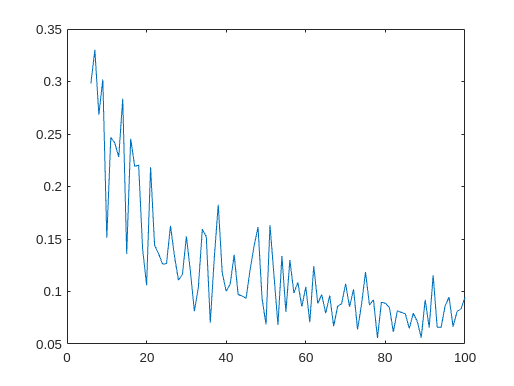

plot(points_num,err)

Random 3d points

function points_array =  random_3d_points(num,min,max)
    points_array = [randi([min, max]);randi([min, max]);randi([min, max]);1];
    for i = 1:num-1
        points_array = cat(2,points_array,[randi([min, max]);randi([min, max]);randi([min, max]);1]);
    end
       % 
end

Intrinsic from P matrix

function [K,cRw] = get_intrinsics_from_proj_matrix(P)
    % Get left-side 3x3 block of P
    M = P(:,1:3);
    % This implements the RQ decomposition from QR in matlab
    [Q,R] = qr(rot90(M,3));
    R = rot90(R,2)';
    Q = rot90(Q);
    % Check the determinant of Q to make cRw a proper rotation
    if det(Q) < 0
        cRw = -Q;
    else
        cRw = Q;
    end
    % Get the normalized intrinsics
    K = R/R(3,3);
end

Point 2d from 3d 

function [points_2d_array] = points_2d_from_3d(points_3d_array,P)
    points_2d_array =P*points_3d_array;
    norm_matrix = [points_2d_array(3,:).^-1;points_2d_array(3,:).^-1;points_2d_array(3,:).^-1] 
    
    points_2d_array = points_2d_array .* norm_matrix
   
end

Add noise

function [points_2d_array_noised] = add_noise_2d(points_2d_array)
    num_points = size( points_2d_array,2)
    noise = [normrnd(0,0.5,[2,num_points]); zeros(1,num_points)] 
    points_2d_array_noised = points_2d_array + noise
end
   



P_from_2d 

function [P_cal] = calibrate_P(points_2d_array,points_3d_array)   
    Q = [];
    B = [];
    for i = 1:size(points_2d_array,2)
        p2d = points_2d_array(:,i);
        p3d = points_3d_array(:,i);
    
        Q1 = [p3d(1), p3d(2), p3d(3), 1, 0, 0, 0, 0, -p2d(1)*p3d(1), -p2d(1)*p3d(2), -p2d(1)*p3d(3)];
        Q2 = [0, 0, 0, 0, p3d(1), p3d(2), p3d(3), 1, -p2d(2)*p3d(1), -p2d(2)*p3d(2), - p2d(2)*p3d(3)];
    
        B1 = [p2d(1)];
        B2 = [p2d(2)];
    
        Q(2*i-1,:) = Q1;
        Q(2*i,:)   = Q2;
        B(2*i-1,:) = B1;
        B(2*i,:)   = B2;
    
    end
    A = inv(Q.'*Q)*Q.'*B;
    P_cal = [A(1), A(2), A(3), A(4);
             A(5), A(6), A(7), A(8);
             A(9), A(10),A(11), 1];
end

Average projection error

function [avg_err] = avg_project_error(points_2d_noise_pojected,ref)    
    diff = points_2d_noise_pojected - ref;
    ecu_dis = [];
    for i=1:size(ref,2)
        ecu_dis(end+1) = sqrt(diff(1,i)^2+ diff(2,i)^2 )  ;
    end
    avg_err = mean(ecu_dis);
end

Generate error plot